## 26617 - FM320 Summative

The following section calculates the multivariate conditional covariance for the returns on the 02/01/2020 then uses this to compute the VaR.

clear
clc

% Reading dataset
[data, dates] = xlsread('Project Data MT 2021.xlsx', 'D9:Z2524');

% Extracting returns for MSFT, JPM, BAC, and UNH respectively
returns = data(:,[1,10,12,19])

returns =     0.0153    0.0291    0.0410    0.0339
    0.0003    0.0192    0.0320   -0.0016
   -0.0062    0.0055    0.0117    0.0098
   -0.0105    0.0196    0.0324    0.0377
    0.0069   -0.0025   -0.0089   -0.0094
   -0.0128   -0.0034    0.0089    0.0067
   -0.0066   -0.0236   -0.0342   -0.0268
    0.0093    0.0173    0.0158    0.0152
    0.0199    0.0099    0.0120    0.0237
   -0.0032   -0.0229   -0.0339    0.0128



% I extracted the dates then converted them to MATLAB date serial numbers
dnr = dates(:,23)

dnr = 2516×1 cell array
    {'2010-01-04'}
    {'2010-01-05'}
    {'2010-01-06'}
    {'2010-01-07'}
    {'2010-01-08'}
    {'2010-01-11'}
    {'2010-01-12'}
    {'2010-01-13'}
    {'2010-01-14'}
    {'2010-01-15'}
    {'2010-01-19'}
    {'2010-01-20'}
    {'2010-01-21'}
    {'2010-01-22'}
    {'2010-01-25'}
    {'2010-01-26'}
    {'2010-01-27'}
    {'2010-01-28'}
    {'2010-01-29'}
    {'2010-02-01'}
    {'2010-02-02'}
    {'2010-02-03'}
    {'2010-02-04'}
    {'2010-02-05'}
    {'2010-02-08'}
    {'2010-02-09'}
    {'2010-02-10'}
    {'2010-02-11'}
    {'2010-02-12'}
    {'2010-02-16'}


dnr2 = datenum(dnr)

dnr2 =       734142
      734143
      734144
      734145
      734146
      734149
      734150
      734151
      734152
      734153



% De-meaning the returns
returns = returns - mean(returns)

returns =     0.0146    0.0285    0.0406    0.0329
   -0.0004    0.0186    0.0316   -0.0025
   -0.0069    0.0049    0.0113    0.0088
   -0.0112    0.0190    0.0320    0.0367
    0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119



% Using dcc function from MFE-Toolbox to calculate the conditional covariance matrix
[parDCC,~,hDCC] = dcc(returns,[],1,0,1); 

____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.215896e+04    0.000e+00    4.876e+02
    1      12    1.215859e+04    0.000e+00    2.417e+02    1.038e-02
    2      17    1.215854e+04    0.000e+00    

 
% Extracting conditional covariance matrix for 02/01/2020
last_Cov = hDCC(:,:,2516)

last_Cov = 	1.0e+-3 *

    0.1341    0.0516    0.0549    0.0494
    0.0516    0.1084    0.1064    0.0472
    0.0549    0.1064    0.1450    0.0543
    0.0494    0.0472    0.0543    0.1436



% Defining the portfolio weights
w = [0.25, 0.25, 0.25, 0.25]


% Calculating portfolio volatility for the last day
last_Vol = sqrt(w*last_Cov*w')

% By assuming normality of returns, I have calculated the 5% VaR in returns
last_VaR = -norminv(0.05)*last_Vol

## Plotting Portfolio Volatility

portfolio_volatility =[]

% Extracting portfolio conditional volatility for each day
for i=1:2516
portfolio_volatility(i,:) = sqrt(w*hDCC(:,:,i)*w')
end

% Plotting portfolio volatility against date
figure()
plot(dnr2,portfolio_volatility)
datetick('x',12,'keeplimits')
ylabel('Portfolio Volatility')
title('Portfolio Volatility over Time')

## QQ-plot for Normality of Portfolio Returns

I calculated the portfolio returns by multiplying the returns by the portfolio weights. I then created a QQ-plot of the portfolio returns against the normal.

% Calculating Portfolio returns for each day
portfolio_returns = returns * w'


portfolio_returns =     0.0292
    0.0118
    0.0045
    0.0191
   -0.0041
   -0.0008
   -0.0235
    0.0137
    0.0157
   -0.0125


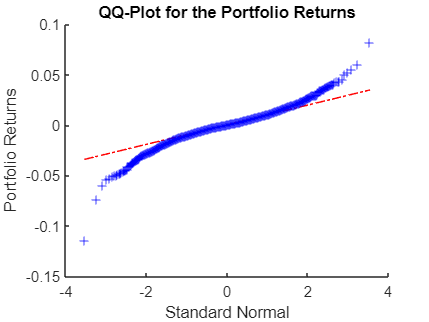

figure()
qqplot(portfolio_returns)
title('QQ-Plot for the Portfolio Returns')
xlabel('Standard Normal')
ylabel('Portfolio Returns')

## Backtesting VaR on a 100 day window 

% Allocating empty vector to store the hit sequence for VaR violations
hit_seq = []


hit_seq =

     []




% I am using a window length of 100 days
window = 100

window = 100


% Creating for loop to calculate VaR for each day from day 101 onwards
for i = 101:2515
    % Extracting the returns for the window of interest
    returns2 = returns((i-window):(i-1),:)  
    [parDCC2,~,hDCC2] = dcc(returns2,[],1,0,1)

    Cov = hDCC2(:,:,100)   
    Vol = sqrt(w*Cov*w')

    % Calculating VaR at day i
    VaR = -norminv(0.05)*Vol

    % Calculating the portfolio returns for day 'i+1'
    portfolio_returns = returns(i+1,:)*w'  
    
    % Checking if returns on day i+1 violate the VaR calculated from day i
    if portfolio_returns < -VaR
        hit_seq(i-100) = 1
    else
        hit_seq(i-100) = 0
    end
end

returns2 =     0.0146    0.0285    0.0406    0.0329
   -0.0004    0.0186    0.0316   -0.0025
   -0.0069    0.0049    0.0113    0.0088
   -0.0112    0.0190    0.0320    0.0367
    0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.679942e+02    0.000e+00    6.033e+01
    1      10    4.678629e+02    0.000e+00    2.904e+01    8.098e-02
    2      13    4.677775e+02    0.000e+00    

parDCC2 =     0.0000    0.2030    0.7968    0.0000    0.1020    0.8435    0.0000    0.0855    0.8726    0.0000    0.0000    0.9605    0.5224    0.5135    0.3209    0.8752    0.3754    0.3766    0.0093    0.9099


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1268    0.0815    0.0825    0.0737
    0.0815    0.3318    0.4528    0.2290
    0.0825    0.4528    0.6810    0.3742
    0.0737    0.2290    0.3742    0.5063


hDCC2(:,:,2) =

   1.0e-03 *

    0.1502    0.1018    0.1065    0.0835
    0.1018    0.3894    0.5158    0.2433
    0.1065    0.5158    0.7617    0.3841
    0.0835    0.2433    0.3841    0.4971


hDCC2(:,:,3) =

   1.0e-03 *

    0.1258    0.0948    0.1030    0.0760
    0.0948    0.3902    0.5182    0.2335
    0.1030    0.5182    0.7765    0.3693
    0.0760    0.2335    0.3693    0.4882


hDCC2(:,:,4) =

   1.0e-03 *

    0.1161    0.0884    0.0985    0.0719
    0.0884    0.3580    0.4734    0.2165
    0.0985    0.4734    0.7149    0.3413
    0.0719    0.2165    0.3413    0.4797


hDCC2(:,:,5) =

   1.0e-03 *

    0.1241    0.0907    0.1030    0.0688
    0.0907    0.3653    0.4835    0.2146
    0.1030    0.4835    0.7380    0.3385
    0.0688    0.2146    0.3385    0.4715


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.3898    0.2848    0.3319    0.1185
    0.2848    0.7428    0.7515    0.1711
    0.3319    0.7515    0.9805    0.2061
    0.1185    0.1711    0.2061    0.2770


Vol = 0.0196

VaR = 0.0322

portfolio_returns = -0.0169

hit_seq = 0

returns2 =    -0.0004    0.0186    0.0316   -0.0025
   -0.0069    0.0049    0.0113    0.0088
   -0.0112    0.0190    0.0320    0.0367
    0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.689538e+02    0.000e+00    8.952e+01
    1       8    4.685546e+02    0.000e+00    9.359e+01    2.338e-01
    2      11    4.683004e+02    0.000e+00    

parDCC2 =     0.0000    0.2121    0.7877    0.0000    0.1239    0.8187    0.0000    0.0944    0.8708    0.0000    0.0000    0.9825    0.5176    0.5044    0.3171    0.8777    0.3797    0.3780    0.0161    0.8693


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1248    0.0259   -0.0035    0.0334
    0.0259    0.2596    0.3451    0.1328
   -0.0035    0.3451    0.5237    0.2247
    0.0334    0.1328    0.2247    0.4106


hDCC2(:,:,2) =

   1.0e-03 *

    0.1050    0.0330    0.0120    0.0346
    0.0330    0.2870    0.3781    0.1352
    0.0120    0.3781    0.5762    0.2237
    0.0346    0.1352    0.2237    0.4077


hDCC2(:,:,3) =

   1.0e-03 *

    0.0996    0.0374    0.0230    0.0359
    0.0374    0.2695    0.3519    0.1302
    0.0230    0.3519    0.5396    0.2120
    0.0359    0.1302    0.2120    0.4048


hDCC2(:,:,4) =

   1.0e-03 *

    0.1118    0.0432    0.0307    0.0329
    0.0432    0.2971    0.3856    0.1427
    0.0307    0.3856    0.5926    0.2276
    0.0329    0.1427    0.2276    0.4019


hDCC2(:,:,5) =

   1.0e-03 *

    0.1027    0.0455    0.0384    0.0341
    0.0455    0.2760    0.3559    0.1358
    0.0384    0.3559    0.5500    0.2145
    0.0341    0.1358    0.2145    0.3991


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.6942    0.3541    0.4149    0.1573
    0.3541    0.6903    0.7101    0.1640
    0.4149    0.7101    0.9345    0.2002
    0.1573    0.1640    0.2002    0.2710


Vol = 0.0203

VaR = 0.0334

portfolio_returns = -0.0120

hit_seq =      0     0


returns2 =    -0.0069    0.0049    0.0113    0.0088
   -0.0112    0.0190    0.0320    0.0367
    0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.664706e+02    0.000e+00    8.961e+01
    1       9    4.657330e+02    0.000e+00    9.091e+01    1.169e-01
    2      12    4.654629e+02    0.000e+00    

parDCC2 =     0.0000    0.2029    0.7969    0.0000    0.1024    0.8515    0.0000    0.0905    0.8729    0.0000    0.0000    0.9512    0.5281    0.5164    0.3203    0.8758    0.3692    0.3776    0.0163    0.8844


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1480    0.1010    0.0710    0.0932
    0.1010    0.4272    0.4785    0.2889
    0.0710    0.4785    0.6134    0.3908
    0.0932    0.2889    0.3908    0.5424


hDCC2(:,:,2) =

   1.0e-03 *

    0.1338    0.0933    0.0711    0.0860
    0.0933    0.3895    0.4391    0.2644
    0.0711    0.4391    0.5727    0.3594
    0.0860    0.2644    0.3594    0.5292


hDCC2(:,:,3) =

   1.0e-03 *

    0.1382    0.0931    0.0748    0.0778
    0.0931    0.3921    0.4556    0.2573
    0.0748    0.4556    0.6185    0.3616
    0.0778    0.2573    0.3616    0.5167


hDCC2(:,:,4) =

   1.0e-03 *

    0.1238    0.0861    0.0737    0.0723
    0.0861    0.3581    0.4172    0.2359
    0.0737    0.4172    0.5735    0.3322
    0.0723    0.2359    0.3322    0.5048


hDCC2(:,:,5) =

   1.0e-03 *

    0.1420    0.0904    0.0795    0.0750
    0.0904    0.3298    0.3834    0.2170
    0.0795    0.3834    0.5329    0.3059
    0.0750    0.2170    0.3059    0.4935


hDCC2(:,:,6)

Cov =     0.0008    0.0004    0.0005    0.0002
    0.0004    0.0008    0.0008    0.0002
    0.0005    0.0008    0.0010    0.0002
    0.0002    0.0002    0.0002    0.0003


Vol = 0.0216

VaR = 0.0355

portfolio_returns = 0.0265

hit_seq =      0     0     0


returns2 =    -0.0112    0.0190    0.0320    0.0367
    0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.674121e+02    0.000e+00    7.003e+01
    1       9    4.668043e+02    0.000e+00    7.449e+01    1.169e-01
    2      12    4.665250e+02    0.000e+00    

parDCC2 =     0.0000    0.1935    0.8063    0.0000    0.0968    0.8623    0.0000    0.0873    0.8725    0.0000    0.0000    0.9436    0.5301    0.5263    0.3250    0.8745    0.3599    0.3721    0.0179    0.8804


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2061    0.1670    0.1572    0.1173
    0.1670    0.5183    0.5733    0.3124
    0.1572    0.5733    0.7171    0.4118
    0.1173    0.3124    0.4118    0.5865


hDCC2(:,:,2) =

   1.0e-03 *

    0.1959    0.1563    0.1519    0.1037
    0.1563    0.5017    0.5699    0.2966
    0.1519    0.5699    0.7412    0.4038
    0.1037    0.2966    0.4038    0.5687


hDCC2(:,:,3) =

   1.0e-03 *

    0.1707    0.1388    0.1385    0.0945
    0.1388    0.4532    0.5159    0.2695
    0.1385    0.5159    0.6802    0.3681
    0.0945    0.2695    0.3681    0.5519


hDCC2(:,:,4) =

   1.0e-03 *

    0.1786    0.1357    0.1364    0.0936
    0.1357    0.4119    0.4684    0.2455
    0.1364    0.4684    0.6257    0.3362
    0.0936    0.2455    0.3362    0.5360


hDCC2(:,:,5) =

   1.0e-03 *

    0.1600    0.1331    0.1395    0.0898
    0.1331    0.4316    0.4970    0.2459
    0.1395    0.4970    0.6766    0.3400
    0.0898    0.2459    0.3400    0.5210


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.6807    0.3754    0.4417    0.1651
    0.3754    0.7106    0.7270    0.1680
    0.4417    0.7270    0.9463    0.2093
    0.1651    0.1680    0.2093    0.2715


Vol = 0.0206

VaR = 0.0339

portfolio_returns = 0.0046

hit_seq =      0     0     0     0


returns2 =     0.0061   -0.0030   -0.0093   -0.0104
   -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.663271e+02    0.000e+00    6.488e+01
    1       8    4.660179e+02    0.000e+00    7.338e+01    2.338e-01
    2      11    4.658892e+02    0.000e+00    

parDCC2 =     0.0000    0.1919    0.8079    0.0000    0.0958    0.8626    0.0000    0.0870    0.8727    0.0003    0.0000    0.0000    0.5439    0.5452    0.3532    0.8759    0.3746    0.3813    0.0129    0.8783


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2139    0.1990    0.2021    0.1336
    0.1990    0.5186    0.5445    0.2180
    0.2021    0.5445    0.6447    0.2613
    0.1336    0.2180    0.2613    0.3257


hDCC2(:,:,2) =

   1.0e-03 *

    0.1853    0.1741    0.1801    0.1201
    0.1741    0.4677    0.4942    0.2021
    0.1801    0.4942    0.5966    0.2445
    0.1201    0.2021    0.2445    0.3257


hDCC2(:,:,3) =

   1.0e-03 *

    0.1903    0.1664    0.1735    0.1170
    0.1664    0.4245    0.4501    0.1878
    0.1735    0.4501    0.5535    0.2291
    0.1170    0.1878    0.2291    0.3257


hDCC2(:,:,4) =

   1.0e-03 *

    0.1695    0.1596    0.1733    0.1085
    0.1596    0.4419    0.4813    0.1907
    0.1733    0.4813    0.6138    0.2398
    0.1085    0.1907    0.2398    0.3257


hDCC2(:,:,5) =

   1.0e-03 *

    0.1562    0.1503    0.1630    0.1025
    0.1503    0.4276    0.4592    0.1846
    0.1630    0.4592    0.5827    0.2284
    0.1025    0.1846    0.2284    0.3257


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.5552    0.3385    0.3903    0.1629
    0.3385    0.6992    0.6963    0.1840
    0.3903    0.6963    0.8883    0.2172
    0.1629    0.1840    0.2172    0.3257


Vol = 0.0201

VaR = 0.0330

portfolio_returns = -0.0288

hit_seq =      0     0     0     0     0


returns2 =    -0.0136   -0.0039    0.0085    0.0057
   -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.677067e+02    0.000e+00    5.571e+01
    1       8    4.678148e+02    0.000e+00    5.716e+01    2.338e-01
    2      11    4.675447e+02    0.000e+00    

parDCC2 =     0.0000    0.1874    0.8108    0.0000    0.0934    0.8628    0.0000    0.0842    0.8706    0.0000    0.0000    0.9441    0.5404    0.5469    0.3570    0.8748    0.3535    0.3683    0.0168    0.8819


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2290    0.2183    0.2270    0.1719
    0.2183    0.5850    0.6062    0.2919
    0.2270    0.6062    0.7028    0.3338
    0.1719    0.2919    0.3338    0.4939


hDCC2(:,:,2) =

   1.0e-03 *

    0.2253    0.2028    0.2120    0.1617
    0.2028    0.5250    0.5458    0.2648
    0.2120    0.5458    0.6453    0.3065
    0.1617    0.2648    0.3065    0.4824


hDCC2(:,:,3) =

   1.0e-03 *

    0.1981    0.1897    0.2058    0.1469
    0.1897    0.5265    0.5622    0.2591
    0.2058    0.5622    0.6900    0.3107
    0.1469    0.2591    0.3107    0.4715


hDCC2(:,:,4) =

   1.0e-03 *

    0.1794    0.1753    0.1903    0.1359
    0.1753    0.4993    0.5278    0.2441
    0.1903    0.5278    0.6480    0.2904
    0.1359    0.2441    0.2904    0.4613


hDCC2(:,:,5) =

   1.0e-03 *

    0.2194    0.1838    0.2027    0.1490
    0.1838    0.4577    0.4849    0.2256
    0.2027    0.4849    0.6027    0.2702
    0.1490    0.2256    0.2702    0.4516


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.5340    0.3261    0.3804    0.1605
    0.3261    0.6657    0.6649    0.1697
    0.3804    0.6649    0.8458    0.2051
    0.1605    0.1697    0.2051    0.2888


Vol = 0.0196

VaR = 0.0322

portfolio_returns = -0.0192

hit_seq =      0     0     0     0     0     0


returns2 =    -0.0074   -0.0242   -0.0346   -0.0277
    0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.676455e+02    0.000e+00    6.579e+01
    1       8    4.678298e+02    0.000e+00    5.586e+01    2.338e-01
    2      11    4.674933e+02    0.000e+00    

parDCC2 =     0.0000    0.1860    0.8138    0.0000    0.1041    0.8564    0.0000    0.0867    0.8671    0.0000    0.0000    0.9289    0.5527    0.5589    0.3573    0.8744    0.3440    0.3624    0.0173    0.8845


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2298    0.2384    0.2662    0.1987
    0.2384    0.6639    0.6945    0.3461
    0.2662    0.6945    0.7953    0.3919
    0.1987    0.3461    0.3919    0.5635


hDCC2(:,:,2) =

   1.0e-03 *

    0.2022    0.2197    0.2518    0.1781
    0.2197    0.6474    0.6918    0.3289
    0.2518    0.6918    0.8209    0.3844
    0.1781    0.3289    0.3844    0.5437


hDCC2(:,:,3) =

   1.0e-03 *

    0.1832    0.2007    0.2292    0.1624
    0.2007    0.6014    0.6373    0.3033
    0.2292    0.6373    0.7596    0.3531
    0.1624    0.3033    0.3531    0.5254


hDCC2(:,:,4) =

   1.0e-03 *

    0.2224    0.2075    0.2395    0.1743
    0.2075    0.5419    0.5762    0.2750
    0.2395    0.5762    0.6976    0.3233
    0.1743    0.2750    0.3233    0.5083


hDCC2(:,:,5) =

   1.0e-03 *

    0.1890    0.1893    0.2237    0.1525
    0.1893    0.5391    0.5863    0.2552
    0.2237    0.5863    0.7338    0.3051
    0.1525    0.2552    0.3051    0.4924


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.4808    0.3008    0.3450    0.1529
    0.3008    0.6232    0.6085    0.1523
    0.3450    0.6085    0.7587    0.1851
    0.1529    0.1523    0.1851    0.2854


Vol = 0.0188

VaR = 0.0309

portfolio_returns = 0.0165

hit_seq =      0     0     0     0     0     0     0


returns2 =     0.0085    0.0167    0.0154    0.0142
    0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.681845e+02    0.000e+00    6.491e+01
    1       8    4.681338e+02    0.000e+00    5.545e+01    2.338e-01
    2      11    4.678238e+02    0.000e+00    

parDCC2 =     0.0000    0.1824    0.8174    0.0000    0.1026    0.8561    0.0000    0.0863    0.8705    0.0000    0.0000    0.9395    0.5539    0.5608    0.3510    0.8755    0.3351    0.3499    0.0178    0.8781


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2572    0.2353    0.2460    0.1809
    0.2353    0.6493    0.6509    0.3002
    0.2460    0.6509    0.7140    0.3140
    0.1809    0.3002    0.3140    0.5113


hDCC2(:,:,2) =

   1.0e-03 *

    0.2283    0.2136    0.2246    0.1642
    0.2136    0.6027    0.6024    0.2778
    0.2246    0.6024    0.6686    0.2920
    0.1642    0.2778    0.2920    0.4972


hDCC2(:,:,3) =

   1.0e-03 *

    0.2583    0.2145    0.2298    0.1714
    0.2145    0.5430    0.5468    0.2526
    0.2298    0.5468    0.6202    0.2706
    0.1714    0.2526    0.2706    0.4840


hDCC2(:,:,4) =

   1.0e-03 *

    0.2188    0.1959    0.2176    0.1503
    0.1959    0.5393    0.5617    0.2344
    0.2176    0.5617    0.6676    0.2575
    0.1503    0.2344    0.2575    0.4715


hDCC2(:,:,5) =

   1.0e-03 *

    0.1926    0.1730    0.1946    0.1361
    0.1730    0.4896    0.5067    0.2029
    0.1946    0.5067    0.6087    0.2327
    0.1361    0.2029    0.2327    0.4599


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.7103    0.4046    0.4330    0.1775
    0.4046    0.7035    0.6552    0.1559
    0.4330    0.6552    0.7773    0.1788
    0.1775    0.1559    0.1788    0.2792


Vol = 0.0201

VaR = 0.0331

portfolio_returns = -0.0165

hit_seq =      0     0     0     0     0     0     0     0


returns2 =     0.0192    0.0093    0.0116    0.0227
   -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.694048e+02    0.000e+00    6.515e+01
    1       7    4.696908e+02    0.000e+00    3.479e+01    4.677e-01
    2      10    4.694765e+02    0.000e+00    

parDCC2 =     0.0000    0.1772    0.8200    0.0000    0.1075    0.8501    0.0000    0.0897    0.8672    0.0000    0.0000    0.9287    0.5450    0.5511    0.3410    0.8753    0.3344    0.3496    0.0190    0.8740


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3215    0.2600    0.2710    0.2001
    0.2600    0.6830    0.6875    0.3139
    0.2710    0.6875    0.7588    0.3299
    0.2001    0.3139    0.3299    0.5417


hDCC2(:,:,2) =

   1.0e-03 *

    0.3333    0.2496    0.2653    0.1985
    0.2496    0.6082    0.6167    0.2821
    0.2653    0.6167    0.6966    0.3020
    0.1985    0.2821    0.3020    0.5229


hDCC2(:,:,3) =

   1.0e-03 *

    0.2808    0.2257    0.2486    0.1730
    0.2257    0.5944    0.6218    0.2583
    0.2486    0.6218    0.7357    0.2835
    0.1730    0.2583    0.2835    0.5055


hDCC2(:,:,4) =

   1.0e-03 *

    0.2437    0.1974    0.2204    0.1544
    0.1974    0.5339    0.5553    0.2215
    0.2204    0.5553    0.6655    0.2538
    0.1544    0.2215    0.2538    0.4894


hDCC2(:,:,5) =

   1.0e-03 *

    0.2574    0.1882    0.2119    0.1555
    0.1882    0.4726    0.4979    0.1988
    0.2119    0.4979    0.6126    0.2298
    0.1555    0.1988    0.2298    0.4743


hDCC2(:,:,6)

Cov = 	1.0e+-3 *

    0.6498    0.3799    0.4201    0.1626
    0.3799    0.6839    0.6595    0.1501
    0.4201    0.6595    0.8091    0.1761
    0.1626    0.1501    0.1761    0.2789


Vol = 0.0199

VaR = 0.0327

portfolio_returns = 0.0180

hit_seq =      0     0     0     0     0     0     0     0     0


returns2 =    -0.0040   -0.0234   -0.0342    0.0119
    0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.698801e+02    0.000e+00    5.213e+01
    1       8    4.696367e+02    0.000e+00    6.864e+01    2.289e-01
    2      11    4.695988e+02    0.000e+00    

parDCC2 =     0.0000    0.1743    0.8201    0.0000    0.1140    0.8390    0.0000    0.0920    0.8611    0.0000    0.0000    0.9292    0.5482    0.5535    0.3381    0.8743    0.3345    0.3500    0.0198    0.8808


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3053    0.2698    0.2754    0.1710
    0.2698    0.7473    0.7499    0.3237
    0.2754    0.7499    0.8233    0.3336
    0.1710    0.3237    0.3336    0.5224


hDCC2(:,:,2) =

   1.0e-03 *

    0.2580    0.2408    0.2553    0.1503
    0.2408    0.7089    0.7336    0.2927
    0.2553    0.7336    0.8444    0.3095
    0.1503    0.2927    0.3095    0.5050


hDCC2(:,:,3) =

   1.0e-03 *

    0.2250    0.2090    0.2258    0.1362
    0.2090    0.6249    0.6456    0.2484
    0.2258    0.6456    0.7557    0.2751
    0.1362    0.2484    0.2751    0.4888


hDCC2(:,:,4) =

   1.0e-03 *

    0.2415    0.1987    0.2172    0.1398
    0.1987    0.5441    0.5704    0.2208
    0.2172    0.5704    0.6876    0.2477
    0.1398    0.2208    0.2477    0.4738


hDCC2(:,:,5) =

    0.0003    0.0003    0.0003    0.0002
    0.0003    0.0010    0.0009    0.0003
    0.0003    0.0009    0.0010    0.0003
    0.0002    0.0003    0.0003    0.0005


hDCC2(:,:,6) =

    0.0005

Cov = 	1.0e+-3 *

    0.5413    0.3378    0.3748    0.1442
    0.3378    0.6755    0.6571    0.1537
    0.3748    0.6571    0.8100    0.1815
    0.1442    0.1537    0.1815    0.2770


Vol = 0.0194

VaR = 0.0319

portfolio_returns = 0.0065

hit_seq =      0     0     0     0     0     0     0     0     0     0


returns2 =     0.0070   -0.0098    0.0033    0.0391
   -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.688377e+02    0.000e+00    5.753e+01
    1       9    4.683172e+02    0.000e+00    6.170e+01    1.144e-01
    2      12    4.681848e+02    0.000e+00    

parDCC2 =     0.0000    0.1698    0.8161    0.0000    0.1183    0.8340    0.0000    0.0884    0.8654    0.0000    0.0000    0.9060    0.5483    0.5567    0.3378    0.8755    0.3376    0.3601    0.0207    0.8864


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3307    0.2785    0.2777    0.1830
    0.2785    0.7678    0.7268    0.4146
    0.2777    0.7268    0.7483    0.4194
    0.1830    0.4146    0.4194    0.5823


hDCC2(:,:,2) =

   1.0e-03 *

    0.2837    0.2393    0.2444    0.1629
    0.2393    0.6712    0.6396    0.3478
    0.2444    0.6396    0.6758    0.3667
    0.1629    0.3478    0.3667    0.5535


hDCC2(:,:,3) =

   1.0e-03 *

    0.2877    0.2211    0.2299    0.1610
    0.2211    0.5800    0.5654    0.3024
    0.2299    0.5654    0.6209    0.3254
    0.1610    0.3024    0.3254    0.5275


hDCC2(:,:,4) =

    0.0003    0.0003    0.0003    0.0002
    0.0003    0.0011    0.0009    0.0004
    0.0003    0.0009    0.0009    0.0004
    0.0002    0.0004    0.0004    0.0005


hDCC2(:,:,5) =

    0.0005    0.0004    0.0004    0.0002
    0.0004    0.0011    0.0009    0.0004
    0.0004    0.0009    0.0010    0.0004
    0.0002    0.0004    0.0004    0.0005


hDCC2(:,:,6) =

   1.0e-03 *

    0.4209

Cov = 	1.0e+-3 *

    0.4609    0.3017    0.3410    0.1353
    0.3017    0.6239    0.6166    0.1516
    0.3410    0.6166    0.7689    0.1840
    0.1353    0.1516    0.1840    0.2766


Vol = 0.0187

VaR = 0.0307

portfolio_returns = -0.0110

hit_seq =      0     0     0     0     0     0     0     0     0     0     0


returns2 =    -0.0173    0.0022    0.0100   -0.0176
   -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.648753e+02    0.000e+00    4.961e+01
    1      11    4.648993e+02    0.000e+00    1.661e+01    5.072e-02
    2      15    4.648610e+02    0.000e+00    

parDCC2 =     0.0000    0.1721    0.8140    0.0000    0.1267    0.8182    0.0000    0.0927    0.8550    0.0000    0.0000    0.9527    0.5428    0.5552    0.3354    0.8735    0.3515    0.3658    0.0221    0.9071


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3581    0.3054    0.2975    0.1522
    0.3054    0.8253    0.7963    0.4880
    0.2975    0.7963    0.8178    0.4372
    0.1522    0.4880    0.4372    0.4510


hDCC2(:,:,2) =

   1.0e-03 *

    0.3483    0.2731    0.2725    0.1513
    0.2731    0.6973    0.6898    0.4231
    0.2725    0.6898    0.7378    0.3893
    0.1513    0.4231    0.3893    0.4419


hDCC2(:,:,3) =

    0.0004    0.0004    0.0003    0.0002
    0.0004    0.0012    0.0011    0.0005
    0.0003    0.0011    0.0010    0.0005
    0.0002    0.0005    0.0005    0.0004


hDCC2(:,:,4) =

    0.0005    0.0004    0.0004    0.0002
    0.0004    0.0012    0.0011    0.0005
    0.0004    0.0011    0.0011    0.0004
    0.0002    0.0005    0.0004    0.0004


hDCC2(:,:,5) =

   1.0e-03 *

    0.4549    0.3792    0.3711    0.1644
    0.3792    0.9648    0.9011    0.4448
    0.3711    0.9011    0.9327    0.3982
    0.1644    0.4448    0.3982    0.4173


hDCC2(:,:,6) =

   1.0e-03 *

    0.3808

Cov = 	1.0e+-3 *

    0.3904    0.2797    0.3117    0.1248
    0.2797    0.6369    0.6167    0.1562
    0.3117    0.6167    0.7477    0.1833
    0.1248    0.1562    0.1833    0.2614


Vol = 0.0183

VaR = 0.0302

portfolio_returns = 0.0269

hit_seq =      0     0     0     0     0     0     0     0     0     0     0     0


returns2 =    -0.0199   -0.0687   -0.0642   -0.0438
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.624773e+02    0.000e+00    6.606e+01
    1      11    4.625195e+02    0.000e+00    1.565e+01    5.250e-02
    2      15    4.625405e+02    0.000e+00    

parDCC2 =     0.0000    0.1679    0.8107    0.0000    0.1438    0.7935    0.0000    0.0992    0.8401    0.0000    0.0000    0.9403    0.5470    0.5620    0.3302    0.8711    0.3451    0.3627    0.0241    0.9040


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3856    0.4152    0.4243    0.1752
    0.4152    0.9942    0.9709    0.5880
    0.4243    0.9709    0.9937    0.5570
    0.1752    0.5880    0.5570    0.4845


hDCC2(:,:,2) =

    0.0004    0.0005    0.0005    0.0002
    0.0005    0.0015    0.0013    0.0007
    0.0005    0.0013    0.0013    0.0006
    0.0002    0.0007    0.0006    0.0005


hDCC2(:,:,3) =

    0.0005    0.0006    0.0006    0.0002
    0.0006    0.0014    0.0013    0.0006
    0.0006    0.0013    0.0012    0.0006
    0.0002    0.0006    0.0006    0.0005


hDCC2(:,:,4) =

    0.0005    0.0005    0.0005    0.0002
    0.0005    0.0011    0.0011    0.0005
    0.0005    0.0011    0.0011    0.0005
    0.0002    0.0005    0.0005    0.0004


hDCC2(:,:,5) =

   1.0e-03 *

    0.3892    0.3976    0.4070    0.1557
    0.3976    0.9768    0.9262    0.4822
    0.4070    0.9262    0.9631    0.4558
    0.1557    0.4822    0.4558    0.4356


hDCC2(:,:,6) =

   1.0e-03 *

    0.3257    0.3401    

Cov = 	1.0e+-3 *

    0.4182    0.2576    0.3022    0.1236
    0.2576    0.5317    0.5226    0.1409
    0.3022    0.5226    0.6501    0.1688
    0.1236    0.1409    0.1688    0.2604


Vol = 0.0175

VaR = 0.0288

portfolio_returns = 0.0013

hit_seq = 1×13
     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0364   -0.0352   -0.0379    0.0008
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.659135e+02    0.000e+00    5.853e+01
    1       9    4.659626e+02    0.000e+00    6.697e+01    1.144e-01
    2      12    4.656695e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1746    0.8214    0.0000    0.1397    0.8151    0.0000    0.0923    0.8598    0.0001    0.0000    0.7723    0.5512    0.5633    0.3243    0.8694    0.3347    0.3495    0.0193    0.8981


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3796    0.2938    0.3135    0.0816
    0.2938    0.4875    0.4899    0.2478
    0.3135    0.4899    0.5436    0.2339
    0.0816    0.2478    0.2339    0.2529


hDCC2(:,:,2) =

   1.0e-03 *

    0.5473    0.3917    0.4086    0.0975
    0.3917    0.5914    0.5778    0.2591
    0.4086    0.5778    0.6285    0.2393
    0.0975    0.2591    0.2393    0.2605


hDCC2(:,:,3) =

   1.0e-03 *

    0.4777    0.3319    0.3586    0.0924
    0.3319    0.5029    0.5047    0.2316
    0.3586    0.5047    0.5711    0.2219
    0.0924    0.2316    0.2219    0.2663


hDCC2(:,:,4) =

   1.0e-03 *

    0.4020    0.2921    0.3126    0.0844
    0.2921    0.4890    0.4806    0.2238
    0.3126    0.4806    0.5389    0.2118
    0.0844    0.2238    0.2118    0.2708


hDCC2(:,:,5) =

   1.0e-03 *

    0.3392    0.2643    0.2880    0.0802
    0.2643    0.4889    0.4888    0.2202
    0.2880    0.4888    0.5624    0.2166
    0.0802    0.2202    0.2166    0.2743


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3873    0.2539    0.2866    0.1176
    0.2539    0.5502    0.5231    0.1422
    0.2866    0.5231    0.6404    0.1637
    0.1176    0.1422    0.1637    0.2861


Vol = 0.0174

VaR = 0.0286

portfolio_returns = -6.2687e-04

hit_seq = 1×14
     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0116    0.0007    0.0050   -0.0058
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.673990e+02    0.000e+00    6.821e+01
    1       9    4.669228e+02    0.000e+00    6.576e+01    1.144e-01
    2      12    4.667268e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1586    0.8412    0.0000    0.1451    0.8066    0.0000    0.0913    0.8553    0.0001    0.0000    0.6769    0.5332    0.5473    0.3291    0.8673    0.3484    0.3620    0.0200    0.8886


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2450    0.1578    0.1715    0.0845
    0.1578    0.3796    0.3811    0.2686
    0.1715    0.3811    0.4497    0.2589
    0.0845    0.2686    0.2589    0.2754


hDCC2(:,:,2) =

   1.0e-03 *

    0.2315    0.1425    0.1617    0.0808
    0.1425    0.3290    0.3403    0.2382
    0.1617    0.3403    0.4183    0.2386
    0.0808    0.2382    0.2386    0.2782


hDCC2(:,:,3) =

   1.0e-03 *

    0.2033    0.1342    0.1482    0.0734
    0.1342    0.3485    0.3445    0.2355
    0.1482    0.3445    0.4084    0.2274
    0.0734    0.2355    0.2274    0.2801


hDCC2(:,:,4) =

   1.0e-03 *

    0.1790    0.1316    0.1467    0.0702
    0.1316    0.3760    0.3752    0.2361
    0.1467    0.3752    0.4506    0.2339
    0.0702    0.2361    0.2339    0.2813


hDCC2(:,:,5) =

   1.0e-03 *

    0.2065    0.1291    0.1473    0.0727
    0.1291    0.3274    0.3397    0.2105
    0.1473    0.3397    0.4287    0.2195
    0.0727    0.2105    0.2195    0.2822


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.6103    0.3161    0.3534    0.1573
    0.3161    0.5453    0.5147    0.1500
    0.3534    0.5147    0.6269    0.1694
    0.1573    0.1500    0.1694    0.2840


Vol = 0.0184

VaR = 0.0302

portfolio_returns = 0.0034

hit_seq = 1×15
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0054   -0.0204   -0.0145   -0.0181
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.697453e+02    0.000e+00    6.530e+01
    1       9    4.693199e+02    0.000e+00    6.372e+01    1.144e-01
    2      12    4.691504e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1579    0.8391    0.0000    0.1461    0.8005    0.0000    0.0943    0.8489    0.0000         0    0.9970    0.5362    0.5484    0.3415    0.8673    0.3468    0.3649    0.0217    0.8875


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2528    0.1813    0.1824    0.1088
    0.1813    0.4238    0.4124    0.3030
    0.1824    0.4124    0.4865    0.2806
    0.1088    0.3030    0.2806    0.3099


hDCC2(:,:,2) =

   1.0e-03 *

    0.2209    0.1652    0.1650    0.0973
    0.1652    0.4232    0.4015    0.2886
    0.1650    0.4015    0.4648    0.2631
    0.0973    0.2886    0.2631    0.3090


hDCC2(:,:,3) =

   1.0e-03 *

    0.1934    0.1567    0.1608    0.0907
    0.1567    0.4347    0.4211    0.2800
    0.1608    0.4211    0.4988    0.2652
    0.0907    0.2800    0.2652    0.3081


hDCC2(:,:,4) =

   1.0e-03 *

    0.2182    0.1501    0.1585    0.0919
    0.1501    0.3727    0.3758    0.2467
    0.1585    0.3758    0.4677    0.2463
    0.0919    0.2467    0.2463    0.3072


hDCC2(:,:,5) =

   1.0e-03 *

    0.3800    0.1937    0.2054    0.1263
    0.1937    0.3516    0.3550    0.2294
    0.2054    0.3550    0.4445    0.2315
    0.1263    0.2294    0.2315    0.3062


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.5272    0.2673    0.3072    0.1351
    0.2673    0.4542    0.4409    0.1244
    0.3072    0.4409    0.5524    0.1454
    0.1351    0.1244    0.1454    0.2304


Vol = 0.0170

VaR = 0.0279

portfolio_returns = -0.0092

hit_seq = 1×16
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0050    0.0223    0.0277    0.0234
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.704385e+02    0.000e+00    6.781e+01
    1       8    4.703356e+02    0.000e+00    7.749e+01    2.289e-01
    2      11    4.702129e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1601    0.8300    0.0000    0.1467    0.7989    0.0000    0.0983    0.8409    0.0002    0.0000    0.4257    0.5422    0.5540    0.3386    0.8630    0.3330    0.3532    0.0198    0.8793


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2713    0.2088    0.2105    0.1280
    0.2088    0.4133    0.4164    0.2704
    0.2105    0.4164    0.5091    0.2573
    0.1280    0.2704    0.2573    0.2867


hDCC2(:,:,2) =

   1.0e-03 *

    0.2340    0.1943    0.1998    0.1148
    0.1943    0.4267    0.4333    0.2599
    0.1998    0.4333    0.5363    0.2542
    0.1148    0.2599    0.2542    0.2822


hDCC2(:,:,3) =

   1.0e-03 *

    0.2514    0.1807    0.1919    0.1123
    0.1807    0.3658    0.3841    0.2273
    0.1919    0.3841    0.4968    0.2333
    0.1123    0.2273    0.2333    0.2802


hDCC2(:,:,4) =

   1.0e-03 *

    0.4088    0.2224    0.2366    0.1446
    0.2224    0.3459    0.3609    0.2105
    0.2366    0.3609    0.4670    0.2173
    0.1446    0.2105    0.2173    0.2794


hDCC2(:,:,5) =

   1.0e-03 *

    0.3529    0.2041    0.2166    0.1317
    0.2041    0.3422    0.3509    0.1981
    0.2166    0.3509    0.4487    0.2040
    0.1317    0.1981    0.2040    0.2791


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.4286    0.2230    0.2593    0.1280
    0.2230    0.3858    0.3777    0.1182
    0.2593    0.3777    0.4847    0.1410
    0.1280    0.1182    0.1410    0.2788


Vol = 0.0160

VaR = 0.0262

portfolio_returns = -0.0134

hit_seq = 1×17
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0181    0.0032    0.0114    0.0047
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.710076e+02    0.000e+00    6.989e+01
    1       8    4.711692e+02    0.000e+00    4.784e+01    2.338e-01
    2      11    4.709272e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1666    0.8216    0.0000    0.1512    0.7896    0.0000    0.1015    0.8311    0.0001    0.0108    0.6232    0.5450    0.5552    0.3390    0.8618    0.3259    0.3446    0.0173    0.8840


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2940    0.2180    0.2157    0.1325
    0.2180    0.3853    0.3743    0.2378
    0.2157    0.3743    0.4522    0.2045
    0.1325    0.2378    0.2045    0.2589


hDCC2(:,:,2) =

   1.0e-03 *

    0.3012    0.1982    0.2043    0.1278
    0.1982    0.3308    0.3347    0.2096
    0.2043    0.3347    0.4251    0.1915
    0.1278    0.2096    0.1915    0.2626


hDCC2(:,:,3) =

   1.0e-03 *

    0.4558    0.2363    0.2446    0.1586
    0.2363    0.3173    0.3197    0.1967
    0.2446    0.3197    0.4062    0.1823
    0.1586    0.1967    0.1823    0.2668


hDCC2(:,:,4) =

   1.0e-03 *

    0.3887    0.2164    0.2234    0.1429
    0.2164    0.3191    0.3166    0.1867
    0.2234    0.3166    0.3975    0.1735
    0.1429    0.1867    0.1735    0.2675


hDCC2(:,:,5) =

   1.0e-03 *

    0.3247    0.2033    0.1986    0.1266
    0.2033    0.3526    0.3234    0.1931
    0.1986    0.3234    0.3793    0.1664
    0.1266    0.1931    0.1664    0.2753


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3527    0.1984    0.2206    0.1125
    0.1984    0.3730    0.3451    0.1076
    0.2206    0.3451    0.4284    0.1259
    0.1125    0.1076    0.1259    0.2699


Vol = 0.0151

VaR = 0.0248

portfolio_returns = -0.0075

hit_seq = 1×18
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0349   -0.0144   -0.0128   -0.0139
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.728073e+02    0.000e+00    4.302e+01
    1       9    4.723903e+02    0.000e+00    5.567e+01    1.144e-01
    2      12    4.722493e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1616    0.8221    0.0000    0.1549    0.7846    0.0000    0.1067    0.8263    0.0000    0.0000    0.9961    0.5505    0.5654    0.3584    0.8624    0.3324    0.3542    0.0194    0.8897


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2797    0.2408    0.2606    0.1667
    0.2408    0.4170    0.4022    0.2535
    0.2606    0.4022    0.4814    0.2310
    0.1667    0.2535    0.2310    0.3162


hDCC2(:,:,2) =

   1.0e-03 *

    0.4326    0.2794    0.3038    0.2018
    0.2794    0.3838    0.3723    0.2327
    0.3038    0.3723    0.4506    0.2164
    0.2018    0.2327    0.2164    0.3149


hDCC2(:,:,3) =

   1.0e-03 *

    0.3698    0.2495    0.2711    0.1805
    0.2495    0.3704    0.3577    0.2173
    0.2711    0.3577    0.4326    0.2041
    0.1805    0.2173    0.2041    0.3137


hDCC2(:,:,4) =

   1.0e-03 *

    0.3096    0.2287    0.2363    0.1569
    0.2287    0.3928    0.3551    0.2178
    0.2363    0.3551    0.4062    0.1918
    0.1569    0.2178    0.1918    0.3125


hDCC2(:,:,5) =

   1.0e-03 *

    0.2643    0.1928    0.2056    0.1364
    0.1928    0.3405    0.3161    0.1935
    0.2056    0.3161    0.3734    0.1770
    0.1364    0.1935    0.1770    0.3113


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3509    0.1865    0.2094    0.1076
    0.1865    0.3226    0.3022    0.0924
    0.2094    0.3022    0.3797    0.1097
    0.1076    0.0924    0.1097    0.2148


Vol = 0.0143

VaR = 0.0236

portfolio_returns = -0.0198

hit_seq = 1×19
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0074    0.0170    0.0153    0.0030
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.705147e+02    0.000e+00    3.382e+01
    1      12    4.701831e+02    0.000e+00    1.038e-01    2.429e-02
    2      17    4.701699e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1318    0.8649    0.0000    0.1579    0.7786    0.0000    0.1149    0.8179    0.0000    0.0000    0.9951    0.5507    0.5831    0.3667    0.8529    0.3172    0.3516    0.0221    0.9094


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1553    0.2305    0.2705    0.0910
    0.2305    0.4570    0.4694    0.2070
    0.2705    0.4694    0.5957    0.1620
    0.0910    0.2070    0.1620    0.3365


hDCC2(:,:,2) =

   1.0e-03 *

    0.1452    0.2107    0.2459    0.0874
    0.2107    0.4263    0.4338    0.1940
    0.2459    0.4338    0.5481    0.1549
    0.0874    0.1940    0.1549    0.3348


hDCC2(:,:,3) =

   1.0e-03 *

    0.1295    0.1948    0.2162    0.0806
    0.1948    0.4358    0.4153    0.1965
    0.2162    0.4153    0.4967    0.1488
    0.0806    0.1965    0.1488    0.3332


hDCC2(:,:,4) =

   1.0e-03 *

    0.1193    0.1678    0.1910    0.0730
    0.1678    0.3719    0.3613    0.1764
    0.1910    0.3613    0.4430    0.1396
    0.0730    0.1764    0.1396    0.3315


hDCC2(:,:,5) =

   1.0e-03 *

    0.2157    0.3158    0.3263    0.1100
    0.3158    0.7080    0.6366    0.2531
    0.3263    0.6366    0.7059    0.1959
    0.1100    0.2531    0.1959    0.3299


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3553    0.1836    0.2097    0.1120
    0.1836    0.3032    0.2799    0.0904
    0.2097    0.2799    0.3486    0.1089
    0.1120    0.0904    0.1089    0.2060


Vol = 0.0141

VaR = 0.0232

portfolio_returns = 0.0113

hit_seq = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0010    0.0224    0.0112    0.0264
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.674498e+02    0.000e+00    4.761e+00
    1      13    4.674057e+02    0.000e+00    9.369e-02    8.223e-03
    2      18    4.673324e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1389    0.8547    0.0000    0.1577    0.7794    0.0000    0.1137    0.8192    0.0000    0.0000    0.9920    0.5494    0.5799    0.3790    0.8545    0.3295    0.3691    0.0223    0.9246


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1645    0.2357    0.2919    0.1075
    0.2357    0.4625    0.4732    0.2129
    0.2919    0.4732    0.6641    0.2115
    0.1075    0.2129    0.2115    0.4100


hDCC2(:,:,2) =

   1.0e-03 *

    0.1449    0.2156    0.2542    0.0987
    0.2156    0.4643    0.4467    0.2151
    0.2542    0.4467    0.5925    0.1996
    0.0987    0.2151    0.1996    0.4067


hDCC2(:,:,3) =

   1.0e-03 *

    0.1317    0.1849    0.2228    0.0895
    0.1849    0.3944    0.3866    0.1943
    0.2228    0.3866    0.5223    0.1853
    0.0895    0.1943    0.1853    0.4035


hDCC2(:,:,4) =

   1.0e-03 *

    0.2313    0.3368    0.3593    0.1293
    0.3368    0.7254    0.6469    0.2740
    0.3593    0.6469    0.7685    0.2412
    0.1293    0.2740    0.2412    0.4002


hDCC2(:,:,5) =

   1.0e-03 *

    0.2063    0.2819    0.3179    0.1210
    0.2819    0.5908    0.5523    0.2419
    0.3179    0.5523    0.6944    0.2264
    0.1210    0.2419    0.2264    0.3970


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3446    0.1687    0.2035    0.1128
    0.1687    0.2927    0.2645    0.0811
    0.2035    0.2645    0.3340    0.1081
    0.1128    0.0811    0.1081    0.1848


Vol = 0.0138

VaR = 0.0226

portfolio_returns = -0.0175

hit_seq = 1×21
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0052   -0.0070   -0.0049   -0.0226
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.715024e+02    0.000e+00    2.533e+00
    1      14    4.714784e+02    0.000e+00    8.442e-02    5.076e-03
    2      18    4.714312e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1518    0.8418    0.0000    0.1555    0.7883    0.0000    0.1204    0.8103    0.0000    0.0000    0.9943    0.5134    0.5510    0.3683    0.8571    0.3152    0.3593    0.0239    0.9250


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1869    0.2569    0.3228    0.1123
    0.2569    0.4478    0.4865    0.1626
    0.3228    0.4865    0.7173    0.1904
    0.1123    0.1626    0.1904    0.3447


hDCC2(:,:,2) =

   1.0e-03 *

    0.1658    0.2181    0.2763    0.0999
    0.2181    0.3849    0.4192    0.1491
    0.2763    0.4192    0.6199    0.1751
    0.0999    0.1491    0.1751    0.3428


hDCC2(:,:,3) =

   1.0e-03 *

    0.2692    0.3789    0.4147    0.1382
    0.3789    0.7152    0.6838    0.2215
    0.4147    0.6838    0.8626    0.2264
    0.1382    0.2215    0.2264    0.3408


hDCC2(:,:,4) =

   1.0e-03 *

    0.2358    0.3150    0.3601    0.1278
    0.3150    0.5886    0.5822    0.1975
    0.3601    0.5822    0.7672    0.2113
    0.1278    0.1975    0.2113    0.3388


hDCC2(:,:,5) =

   1.0e-03 *

    0.2229    0.2857    0.3546    0.1231
    0.2857    0.5299    0.5671    0.1849
    0.3546    0.5671    0.8106    0.2154
    0.1231    0.1849    0.2154    0.3369


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3134    0.1693    0.2049    0.1114
    0.1693    0.3462    0.3143    0.0944
    0.2049    0.3143    0.3904    0.1250
    0.1114    0.0944    0.1250    0.1951


Vol = 0.0143

VaR = 0.0236

portfolio_returns = -0.0370

hit_seq = 1×22
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


returns2 = 100×4
   -0.0287   -0.0499   -0.0519   -0.0271
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.703428e+02    0.000e+00    1.264e+01
    1      13    4.703242e+02    0.000e+00    1.012e-01    1.180e-02
    2      18    4.703172e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1608    0.8285    0.0000    0.1825    0.7559    0.0000    0.1286    0.7970    0.0002    0.0000    0.4329    0.5120    0.5482    0.3609    0.8559    0.3113    0.3445    0.0248    0.9194


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2024    0.2846    0.3493    0.1344
    0.2846    0.4843    0.5185    0.1523
    0.3493    0.5185    0.7779    0.1701
    0.1344    0.1523    0.1701    0.2981


hDCC2(:,:,2) =

    0.0003    0.0005    0.0005    0.0002
    0.0005    0.0008    0.0008    0.0002
    0.0005    0.0008    0.0010    0.0002
    0.0002    0.0002    0.0002    0.0003


hDCC2(:,:,3) =

   1.0e-03 *

    0.2630    0.3671    0.4099    0.1501
    0.3671    0.6693    0.6525    0.1863
    0.4099    0.6525    0.8727    0.1913
    0.1501    0.1863    0.1913    0.2771


hDCC2(:,:,4) =

   1.0e-03 *

    0.2441    0.3227    0.3932    0.1415
    0.3227    0.5822    0.6168    0.1712
    0.3932    0.6168    0.8967    0.1925
    0.1415    0.1712    0.1925    0.2744


hDCC2(:,:,5) =

   1.0e-03 *

    0.2221    0.2860    0.3351    0.1337
    0.2860    0.5238    0.5321    0.1633
    0.3351    0.5321    0.7524    0.1725
    0.1337    0.1633    0.1725    0.2732


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.3157    0.1728    0.1919    0.1225
    0.1728    0.5201    0.4052    0.1297
    0.1919    0.4052    0.4290    0.1447
    0.1225    0.1297    0.1447    0.2723


Vol = 0.0156

VaR = 0.0256

portfolio_returns = -0.0124

hit_seq = 1×23
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0


returns2 = 100×4
    0.0057   -0.0019    0.0164    0.0015
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.715412e+02    0.000e+00    6.186e+00
    1      12    4.715521e+02    0.000e+00    1.020e-01    1.661e-02
    2      17    4.714842e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1135    0.8863    0.0000    0.1898    0.7678    0.0000    0.1183    0.8231    0.0003    0.0000    0.0000    0.5217    0.5709    0.3606    0.8509    0.2961    0.3379    0.0216    0.9242


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1041    0.1183    0.1858    0.0463
    0.1183    0.2379    0.2681    0.0542
    0.1858    0.2681    0.5255    0.0645
    0.0463    0.0542    0.0645    0.2708


hDCC2(:,:,2) =

   1.0e-03 *

    0.0993    0.1053    0.1743    0.0459
    0.1053    0.2087    0.2444    0.0517
    0.1743    0.2444    0.4992    0.0659
    0.0459    0.0517    0.0659    0.2708


hDCC2(:,:,3) =

   1.0e-03 *

    0.1064    0.1154    0.1962    0.0487
    0.1154    0.2364    0.2895    0.0570
    0.1962    0.2895    0.5960    0.0769
    0.0487    0.0570    0.0769    0.2708


hDCC2(:,:,4) =

   1.0e-03 *

    0.1083    0.1223    0.1807    0.0523
    0.1223    0.2654    0.2844    0.0666
    0.1807    0.2844    0.5254    0.0738
    0.0523    0.0666    0.0738    0.2708


hDCC2(:,:,5) =

   1.0e-03 *

    0.0995    0.1119    0.1636    0.0507
    0.1119    0.2558    0.2716    0.0629
    0.1636    0.2716    0.4882    0.0708
    0.0507    0.0629    0.0708    0.2708


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3401    0.1998    0.2100    0.1257
    0.1998    0.5516    0.4146    0.1351
    0.2100    0.4146    0.4267    0.1399
    0.1257    0.1351    0.1399    0.2708


Vol = 0.0159

VaR = 0.0261

portfolio_returns = -0.0134

hit_seq = 1×24
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0


returns2 = 100×4
   -0.0115   -0.0164   -0.0357   -0.0050
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.703325e+02    0.000e+00    5.886e+00
    1      13    4.702823e+02    0.000e+00    8.802e-02    8.571e-03
    2      18    4.702287e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1178    0.8820    0.0000    0.1853    0.7698    0.0000    0.1169    0.8222    0.0003    0.0000    0.0000    0.5210    0.5683    0.3624    0.8546    0.2987    0.3415    0.0224    0.9237


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1184    0.1442    0.1993    0.0533
    0.1442    0.2749    0.3053    0.0670
    0.1993    0.3053    0.5482    0.0732
    0.0533    0.0670    0.0732    0.2716


hDCC2(:,:,2) =

   1.0e-03 *

    0.1233    0.1481    0.2175    0.0554
    0.1481    0.2863    0.3389    0.0698
    0.2175    0.3389    0.6343    0.0832
    0.0554    0.0698    0.0832    0.2716


hDCC2(:,:,3) =

   1.0e-03 *

    0.1231    0.1499    0.1983    0.0582
    0.1499    0.3025    0.3230    0.0772
    0.1983    0.3230    0.5565    0.0794
    0.0582    0.0772    0.0794    0.2716


hDCC2(:,:,4) =

   1.0e-03 *

    0.1122    0.1347    0.1781    0.0560
    0.1347    0.2839    0.3025    0.0721
    0.1781    0.3025    0.5132    0.0757
    0.0560    0.0721    0.0757    0.2716


hDCC2(:,:,5) =

   1.0e-03 *

    0.1041    0.1185    0.1593    0.0549
    0.1185    0.2456    0.2665    0.0680
    0.1593    0.2665    0.4579    0.0728
    0.0549    0.0680    0.0728    0.2716


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.5146    0.3103    0.3386    0.1671
    0.3103    0.7359    0.5861    0.1700
    0.3386    0.5861    0.6224    0.1829
    0.1671    0.1700    0.1829    0.2716


Vol = 0.0188

VaR = 0.0309

portfolio_returns = -4.4447e-04

hit_seq = 1×25
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0


returns2 = 100×4
    0.0097    0.0176   -0.0011    0.0171
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.691576e+02    0.000e+00    1.127e+01
    1      12    4.690452e+02    0.000e+00    9.766e-02    1.867e-02
    2      17    4.689736e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1136    0.8862    0.0000    0.1789    0.7739    0.0000    0.1070    0.8369    0.0000    0.0000    0.9870    0.5147    0.5581    0.3790    0.8521    0.3225    0.3764    0.0200    0.9217


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1128    0.1392    0.1694    0.0714
    0.1392    0.2807    0.2737    0.1029
    0.1694    0.2737    0.4510    0.0962
    0.0714    0.1029    0.0962    0.4060


hDCC2(:,:,2) =

   1.0e-03 *

    0.1138    0.1416    0.1581    0.0742
    0.1416    0.2973    0.2669    0.1099
    0.1581    0.2669    0.4104    0.0938
    0.0742    0.1099    0.0938    0.4023


hDCC2(:,:,3) =

   1.0e-03 *

    0.1044    0.1279    0.1454    0.0712
    0.1279    0.2801    0.2567    0.1033
    0.1454    0.2567    0.3953    0.0918
    0.0712    0.1033    0.0918    0.3988


hDCC2(:,:,4) =

   1.0e-03 *

    0.0975    0.1130    0.1326    0.0695
    0.1130    0.2436    0.2310    0.0965
    0.1326    0.2310    0.3646    0.0900
    0.0695    0.0965    0.0900    0.3952


hDCC2(:,:,5) =

   1.0e-03 *

    0.0961    0.1029    0.1289    0.0716
    0.1029    0.2145    0.2148    0.0897
    0.1289    0.2148    0.3554    0.0964
    0.0716    0.0897    0.0964    0.3917


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.4782    0.2734    0.3069    0.1425
    0.2734    0.6128    0.5094    0.1398
    0.3069    0.5094    0.5687    0.1583
    0.1425    0.1398    0.1583    0.2032


Vol = 0.0175

VaR = 0.0289

portfolio_returns = 0.0177

hit_seq = 1×26
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0


returns2 = 100×4
   -0.0015    0.0118    0.0133   -0.0098
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.683746e+02    0.000e+00    3.014e+01
    1       9    4.684036e+02    0.000e+00    2.621e+01    3.247e-02
    2      14    4.684321e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1124    0.8874    0.0000    0.1729    0.7762    0.0000    0.1130    0.8274    0.0000    0.0000    0.9855    0.5105    0.5585    0.3736    0.8593    0.3116    0.3706    0.0178    0.9271


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1085    0.1275    0.1837    0.0565
    0.1275    0.2620    0.2949    0.0734
    0.1837    0.2949    0.4980    0.1056
    0.0565    0.0734    0.1056    0.4059


hDCC2(:,:,2) =

   1.0e-03 *

    0.0998    0.1168    0.1666    0.0553
    0.1168    0.2530    0.2816    0.0707
    0.1666    0.2816    0.4661    0.1021
    0.0553    0.0707    0.1021    0.4021


hDCC2(:,:,3) =

   1.0e-03 *

    0.0936    0.1044    0.1502    0.0549
    0.1044    0.2236    0.2518    0.0681
    0.1502    0.2518    0.4206    0.0986
    0.0549    0.0681    0.0986    0.3983


hDCC2(:,:,4) =

   1.0e-03 *

    0.0927    0.0961    0.1439    0.0582
    0.0961    0.1999    0.2326    0.0654
    0.1439    0.2326    0.4003    0.1028
    0.0582    0.0654    0.1028    0.3946


hDCC2(:,:,5) =

   1.0e-03 *

    0.1254    0.1421    0.2113    0.0580
    0.1421    0.3139    0.3700    0.0684
    0.2113    0.3700    0.6210    0.1053
    0.0580    0.0684    0.1053    0.3910


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.4311    0.2381    0.2858    0.1272
    0.2381    0.5264    0.4765    0.1263
    0.2858    0.4765    0.5738    0.1592
    0.1272    0.1263    0.1592    0.2047


Vol = 0.0169

VaR = 0.0278

portfolio_returns = 0.0305

hit_seq = 1×27
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0


returns2 = 100×4
    0.0039    0.0033   -0.0031    0.0115
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.690727e+02    0.000e+00    1.158e+01
    1      12    4.690460e+02    0.000e+00    2.472e+00    2.191e-02
    2      16    4.689897e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1187    0.8811    0.0000    0.1807    0.7649    0.0000    0.1177    0.8193    0.0000    0.0000    0.9221    0.5132    0.5602    0.3690    0.8592    0.3089    0.3632    0.0227    0.9182


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1187    0.1396    0.2018    0.0619
    0.1396    0.3036    0.3011    0.1198
    0.2018    0.3011    0.5203    0.1386
    0.0619    0.1198    0.1386    0.4310


hDCC2(:,:,2) =

   1.0e-03 *

    0.1098    0.1219    0.1785    0.0605
    0.1219    0.2605    0.2647    0.1091
    0.1785    0.2647    0.4626    0.1291
    0.0605    0.1091    0.1291    0.4171


hDCC2(:,:,3) =

   1.0e-03 *

    0.1068    0.1096    0.1675    0.0632
    0.1096    0.2266    0.2403    0.0990
    0.1675    0.2403    0.4332    0.1293
    0.0632    0.0990    0.1293    0.4042


hDCC2(:,:,4) =

   1.0e-03 *

    0.1396    0.1557    0.2380    0.0596
    0.1557    0.3390    0.3734    0.1007
    0.2380    0.3734    0.6566    0.1262
    0.0596    0.1007    0.1262    0.3923


hDCC2(:,:,5) =

   1.0e-03 *

    0.1334    0.1363    0.2355    0.0622
    0.1363    0.2859    0.3476    0.0892
    0.2355    0.3476    0.6941    0.1451
    0.0622    0.0892    0.1451    0.3813


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3841    0.2031    0.2569    0.1322
    0.2031    0.4364    0.4151    0.1240
    0.2569    0.4151    0.5253    0.1619
    0.1322    0.1240    0.1619    0.2516


Vol = 0.0162

VaR = 0.0266

portfolio_returns = 0.0071

hit_seq = 1×28
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


returns2 = 100×4
   -0.0075   -0.0024   -0.0128   -0.0298
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.666170e+02    0.000e+00    1.061e+01
    1      13    4.665623e+02    0.000e+00    9.194e-02    1.220e-02
    2      19    4.665631e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1274    0.8724    0.0000    0.1747    0.7928    0.0000    0.1376    0.8008    0.0000    0.0000    0.8975    0.5140    0.5620    0.3710    0.8656    0.3080    0.3667    0.0264    0.9144


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1337    0.1434    0.2193    0.0662
    0.1434    0.3313    0.3277    0.1341
    0.2193    0.3277    0.5724    0.1626
    0.0662    0.1341    0.1626    0.4524


hDCC2(:,:,2) =

   1.0e-03 *

    0.1274    0.1273    0.2003    0.0685
    0.1273    0.2856    0.2920    0.1197
    0.2003    0.2920    0.5193    0.1576
    0.0685    0.1197    0.1576    0.4319


hDCC2(:,:,3) =

   1.0e-03 *

    0.1599    0.1691    0.2749    0.0625
    0.1691    0.3831    0.4248    0.1146
    0.2749    0.4248    0.7660    0.1501
    0.0625    0.1146    0.1501    0.4134


hDCC2(:,:,4) =

   1.0e-03 *

    0.1505    0.1478    0.2671    0.0649
    0.1478    0.3260    0.3932    0.1009
    0.2671    0.3932    0.7935    0.1687
    0.0649    0.1009    0.1687    0.3969


hDCC2(:,:,5) =

   1.0e-03 *

    0.1546    0.1403    0.2496    0.0661
    0.1403    0.2934    0.3533    0.0948
    0.2496    0.3533    0.6993    0.1578
    0.0661    0.0948    0.1578    0.3820


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3997    0.2082    0.2617    0.1432
    0.2082    0.4277    0.4072    0.1271
    0.2617    0.4072    0.5081    0.1652
    0.1432    0.1271    0.1652    0.2519


Vol = 0.0162

VaR = 0.0267

portfolio_returns = 0.0090

hit_seq = 1×29
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0


returns2 = 100×4
    0.0188    0.0278    0.0476   -0.0182
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.639998e+02    0.000e+00    1.285e+01
    1      12    4.639703e+02    0.000e+00    6.731e+00    2.423e-02
    2      17    4.639823e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1382    0.8616    0.0000    0.1726    0.7899    0.0000    0.1415    0.7890    0.0000    0.0000    0.9868    0.5117    0.5582    0.3821    0.8664    0.3249    0.3865    0.0256    0.9121


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1562    0.1484    0.2357    0.0457
    0.1484    0.3568    0.3472    0.1354
    0.2357    0.3472    0.6097    0.1349
    0.0457    0.1354    0.1349    0.3823


hDCC2(:,:,2) =

   1.0e-03 *

    0.1873    0.1840    0.3047    0.0413
    0.1840    0.4376    0.4669    0.1278
    0.3047    0.4669    0.8430    0.1255
    0.0413    0.1278    0.1255    0.3791


hDCC2(:,:,3) =

   1.0e-03 *

    0.1732    0.1593    0.2897    0.0474
    0.1593    0.3685    0.4264    0.1132
    0.2897    0.4264    0.8522    0.1492
    0.0474    0.1132    0.1492    0.3760


hDCC2(:,:,4) =

   1.0e-03 *

    0.1744    0.1491    0.2665    0.0511
    0.1491    0.3265    0.3780    0.1069
    0.2665    0.3780    0.7400    0.1433
    0.0511    0.1069    0.1433    0.3729


hDCC2(:,:,5) =

   1.0e-03 *

    0.1621    0.1364    0.2313    0.0554
    0.1364    0.2979    0.3335    0.1057
    0.2313    0.3335    0.6255    0.1323
    0.0554    0.1057    0.1323    0.3698


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3965    0.2841    0.3147    0.1324
    0.2841    0.7568    0.6545    0.1599
    0.3147    0.6545    0.7209    0.1842
    0.1324    0.1599    0.1842    0.2063


Vol = 0.0186

VaR = 0.0306

portfolio_returns = 0.0094

hit_seq = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0077   -0.0013    0.0321    0.0277
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.644246e+02    0.000e+00    5.060e+01
    1       9    4.643818e+02    0.000e+00    3.408e+01    1.144e-01
    2      14    4.643252e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1197    0.8801    0.0000    0.1611    0.8042    0.0000    0.0996    0.8645    0.0000    0.0000    0.9931    0.4974    0.5387    0.4024    0.8551    0.3527    0.4199    0.0333    0.8783


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1168    0.0914    0.1293    0.0949
    0.0914    0.2842    0.1880    0.2115
    0.1293    0.1880    0.3575    0.2701
    0.0949    0.2115    0.2701    0.3727


hDCC2(:,:,2) =

   1.0e-03 *

    0.1132    0.0832    0.1393    0.0953
    0.0832    0.2502    0.1910    0.1809
    0.1393    0.1910    0.4350    0.2932
    0.0953    0.1809    0.2932    0.3703


hDCC2(:,:,3) =

   1.0e-03 *

    0.1216    0.0850    0.1412    0.0962
    0.0850    0.2345    0.1917    0.1676
    0.1412    0.1917    0.4179    0.2739
    0.0962    0.1676    0.2739    0.3678


hDCC2(:,:,4) =

   1.0e-03 *

    0.1174    0.0833    0.1303    0.0962
    0.0833    0.2261    0.1866    0.1607
    0.1303    0.1866    0.3848    0.2452
    0.0962    0.1607    0.2452    0.3653


hDCC2(:,:,5) =

   1.0e-03 *

    0.1073    0.0816    0.1207    0.0834
    0.0816    0.2657    0.2182    0.1783
    0.1207    0.2182    0.3968    0.2464
    0.0834    0.1783    0.2464    0.3629


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3584    0.2415    0.2691    0.1233
    0.2415    0.6180    0.5408    0.1425
    0.2691    0.5408    0.6152    0.1704
    0.1233    0.1425    0.1704    0.1933


Vol = 0.0172

VaR = 0.0284

portfolio_returns = 0.0187

hit_seq = 1×31
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0125    0.0086    0.0136    0.0033
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.637511e+02    0.000e+00    1.742e+01
    1      12    4.636483e+02    0.000e+00    7.723e+00    2.574e-02
    2      17    4.636622e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1195    0.8803    0.0000    0.1640    0.7964    0.0000    0.0687    0.9091    0.0000    0.0000    0.9938    0.4995    0.5354    0.3947    0.8676    0.3557    0.4087    0.0278    0.9044


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1196    0.1018    0.1044    0.0593
    0.1018    0.3091    0.2063    0.2001
    0.1044    0.2063    0.2293    0.1626
    0.0593    0.2001    0.1626    0.3536


hDCC2(:,:,2) =

   1.0e-03 *

    0.1273    0.1005    0.1104    0.0625
    0.1005    0.2808    0.2022    0.1843
    0.1104    0.2022    0.2374    0.1601
    0.0625    0.1843    0.1601    0.3514


hDCC2(:,:,3) =

   1.0e-03 *

    0.1225    0.0960    0.1050    0.0661
    0.0960    0.2625    0.1940    0.1744
    0.1050    0.1940    0.2321    0.1512
    0.0661    0.1744    0.1512    0.3492


hDCC2(:,:,4) =

   1.0e-03 *

    0.1118    0.0931    0.0993    0.0592
    0.0931    0.2950    0.2205    0.1873
    0.0993    0.2205    0.2553    0.1652
    0.0592    0.1873    0.1652    0.3471


hDCC2(:,:,5) =

   1.0e-03 *

    0.1280    0.1155    0.1117    0.0665
    0.1155    0.3567    0.2528    0.1996
    0.1117    0.2528    0.2686    0.1665
    0.0665    0.1996    0.1665    0.3449


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3245    0.2124    0.2465    0.1122
    0.2124    0.5582    0.5137    0.1369
    0.2465    0.5137    0.6064    0.1654
    0.1122    0.1369    0.1654    0.1904


Vol = 0.0167

VaR = 0.0274

portfolio_returns = 0.0031

hit_seq = 1×32
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0077   -0.0100   -0.0004   -0.0242
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.651692e+02    0.000e+00    2.425e+01
    1      11    4.650998e+02    0.000e+00    2.026e+01    5.520e-02
    2      16    4.650531e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1129    0.8869    0.0000    0.1715    0.7917    0.0000    0.0672    0.9114    0.0000    0.0022    0.8611    0.5004    0.5340    0.3783    0.8696    0.3300    0.3868    0.0323    0.8907


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1064    0.0899    0.0838    0.0528
    0.0899    0.3441    0.2261    0.2269
    0.0838    0.2261    0.2366    0.1876
    0.0528    0.2269    0.1876    0.3956


hDCC2(:,:,2) =

   1.0e-03 *

    0.1044    0.0867    0.0815    0.0569
    0.0867    0.3122    0.2141    0.2048
    0.0815    0.2141    0.2319    0.1718
    0.0569    0.2048    0.1718    0.3755


hDCC2(:,:,3) =

   1.0e-03 *

    0.0965    0.0832    0.0776    0.0503
    0.0832    0.3363    0.2378    0.2087
    0.0776    0.2378    0.2550    0.1809
    0.0503    0.2087    0.1809    0.3594


hDCC2(:,:,4) =

   1.0e-03 *

    0.1136    0.1062    0.0921    0.0570
    0.1062    0.3927    0.2683    0.2127
    0.0921    0.2683    0.2685    0.1766
    0.0570    0.2127    0.1766    0.3432


hDCC2(:,:,5) =

   1.0e-03 *

    0.1150    0.1155    0.1015    0.0625
    0.1155    0.4277    0.2999    0.2181
    0.1015    0.2999    0.2991    0.1852
    0.0625    0.2181    0.1852    0.3302


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3518    0.2059    0.2472    0.1244
    0.2059    0.4822    0.4668    0.1349
    0.2472    0.4668    0.5780    0.1733
    0.1244    0.1349    0.1733    0.2443


Vol = 0.0165

VaR = 0.0272

portfolio_returns = 7.6820e-04

hit_seq = 1×33
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0021    0.0197    0.0202    0.0341
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.639384e+02    0.000e+00    3.030e+01
    1      10    4.640987e+02    0.000e+00    2.147e+01    1.038e-01
    2      15    4.641315e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1159    0.8839    0.0000    0.1735    0.7841    0.0000    0.0746    0.8982    0.0000    0.0072    0.8089    0.4970    0.5347    0.3716    0.8724    0.3241    0.3866    0.0347    0.8841


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1070    0.0857    0.0914    0.0320
    0.0857    0.3596    0.2434    0.2119
    0.0914    0.2434    0.2606    0.1900
    0.0320    0.2119    0.1900    0.3642


hDCC2(:,:,2) =

   1.0e-03 *

    0.0986    0.0813    0.0861    0.0293
    0.0813    0.3731    0.2639    0.2116
    0.0861    0.2639    0.2832    0.1964
    0.0293    0.2116    0.1964    0.3479


hDCC2(:,:,3) =

   1.0e-03 *

    0.1159    0.1043    0.1008    0.0373
    0.1043    0.4214    0.2914    0.2104
    0.1008    0.2914    0.2950    0.1884
    0.0373    0.2104    0.1884    0.3270


hDCC2(:,:,4) =

   1.0e-03 *

    0.1170    0.1135    0.1101    0.0454
    0.1135    0.4496    0.3214    0.2135
    0.1101    0.3214    0.3258    0.1953
    0.0454    0.2135    0.1953    0.3134


hDCC2(:,:,5) =

   1.0e-03 *

    0.1072    0.1004    0.1026    0.0446
    0.1004    0.3820    0.2903    0.1859
    0.1026    0.2903    0.3239    0.1794
    0.0446    0.1859    0.1794    0.2987


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3276    0.2190    0.2426    0.1164
    0.2190    0.5694    0.5137    0.1399
    0.2426    0.5137    0.5814    0.1684
    0.1164    0.1399    0.1684    0.2404


Vol = 0.0168

VaR = 0.0276

portfolio_returns = -0.0444

hit_seq = 1×34
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0148   -0.0246   -0.0172   -0.0092
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.665728e+02    0.000e+00    3.098e+01
    1       9    4.664820e+02    0.000e+00    3.659e+01    1.145e-01
    2      13    4.664450e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1289    0.8709    0.0000    0.1685    0.7868    0.0000    0.0640    0.9119    0.0001    0.0123    0.7103    0.5020    0.5386    0.3799    0.8655    0.3150    0.3646    0.0310    0.8763


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1180    0.0966    0.1074    0.0435
    0.0966    0.3382    0.2049    0.1483
    0.1074    0.2049    0.2197    0.1173
    0.0435    0.1483    0.1173    0.2476


hDCC2(:,:,2) =

   1.0e-03 *

    0.1346    0.1192    0.1198    0.0514
    0.1192    0.3918    0.2369    0.1549
    0.1198    0.2369    0.2363    0.1192
    0.0514    0.1549    0.1192    0.2455


hDCC2(:,:,3) =

   1.0e-03 *

    0.1332    0.1268    0.1261    0.0584
    0.1268    0.4246    0.2700    0.1659
    0.1261    0.2700    0.2688    0.1346
    0.0584    0.1659    0.1346    0.2497


hDCC2(:,:,4) =

   1.0e-03 *

    0.1201    0.1108    0.1159    0.0563
    0.1108    0.3633    0.2482    0.1472
    0.1159    0.2482    0.2730    0.1262
    0.0563    0.1472    0.1262    0.2464


hDCC2(:,:,5) =

   1.0e-03 *

    0.1086    0.1166    0.1074    0.0544
    0.1166    0.4779    0.2794    0.1665
    0.1074    0.2794    0.2685    0.1227
    0.0544    0.1665    0.1227    0.2451


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2979    0.1876    0.2240    0.1103
    0.1876    0.4685    0.4513    0.1188
    0.2240    0.4513    0.5585    0.1515
    0.1103    0.1188    0.1515    0.2400


Vol = 0.0159

VaR = 0.0262

portfolio_returns = 1.9934e-04

hit_seq = 1×35
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0098    0.0235    0.0238    0.0234
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.687936e+02    0.000e+00    4.219e+01
    1       8    4.681871e+02    0.000e+00    4.403e+01    2.289e-01
    2      11    4.680474e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1043    0.8955    0.0000    0.1345    0.8375    0.0000    0.0000    0.9998    0.0001    0.0137    0.5817    0.5042    0.5558    0.3884    0.8506    0.3254    0.3966    0.0326    0.8196


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0940    0.0598    0.0777    0.0338
    0.0598    0.2871    0.1611    0.1328
    0.0777    0.1611    0.1831    0.1008
    0.0338    0.1328    0.1008    0.2566


hDCC2(:,:,2) =

   1.0e-03 *

    0.0976    0.0758    0.0831    0.0449
    0.0758    0.3323    0.1895    0.1458
    0.0831    0.1895    0.1917    0.1106
    0.0449    0.1458    0.1106    0.2573


hDCC2(:,:,3) =

   1.0e-03 *

    0.0912    0.0722    0.0788    0.0456
    0.0722    0.3006    0.1825    0.1300
    0.0788    0.1825    0.2003    0.1035
    0.0456    0.1300    0.1035    0.2507


hDCC2(:,:,4) =

   1.0e-03 *

    0.0854    0.0806    0.0773    0.0461
    0.0806    0.4041    0.2159    0.1466
    0.0773    0.2159    0.2089    0.1041
    0.0461    0.1466    0.1041    0.2481


hDCC2(:,:,5) =

   1.0e-03 *

    0.0934    0.0776    0.0807    0.0500
    0.0776    0.3584    0.2116    0.1302
    0.0807    0.2116    0.2175    0.1035
    0.0500    0.1302    0.1035    0.2451


hDCC2(:,:,6)

Cov = 4×4
    0.0003    0.0002    0.0003    0.0001
    0.0002    0.0004    0.0006    0.0001
    0.0003    0.0006    0.0010    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0175

VaR = 0.0288

portfolio_returns = 0.0086

hit_seq = 1×36
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0018   -0.0057    0.0130   -0.0060
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.718585e+02    0.000e+00    4.563e+01
    1       8    4.708632e+02    0.000e+00    3.386e+01    2.289e-01
    2      12    4.708876e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1014    0.8984    0.0000    0.0775    0.9047    0.0000    0.0000    0.9998    0.0001    0.0150    0.7112    0.4954    0.5343    0.3815    0.8392    0.3179    0.3584    0.0402    0.7811


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0888    0.0332    0.0487    0.0123
    0.0332    0.2193    0.0851    0.0765
    0.0487    0.0851    0.1122    0.0373
    0.0123    0.0765    0.0373    0.2177


hDCC2(:,:,2) =

   1.0e-03 *

    0.0836    0.0395    0.0473    0.0210
    0.0395    0.2127    0.0904    0.0759
    0.0473    0.0904    0.1223    0.0380
    0.0210    0.0759    0.0380    0.2235


hDCC2(:,:,3) =

   1.0e-03 *

    0.0789    0.0483    0.0494    0.0277
    0.0483    0.2818    0.1178    0.0947
    0.0494    0.1178    0.1323    0.0472
    0.0277    0.0947    0.0472    0.2289


hDCC2(:,:,4) =

   1.0e-03 *

    0.0875    0.0507    0.0545    0.0355
    0.0507    0.2679    0.1271    0.0892
    0.0545    0.1271    0.1423    0.0529
    0.0355    0.0892    0.0529    0.2312


hDCC2(:,:,5) =

   1.0e-03 *

    0.1236    0.0638    0.0755    0.0462
    0.0638    0.2567    0.1344    0.0862
    0.0755    0.1344    0.1524    0.0579
    0.0462    0.0862    0.0579    0.2327


hDCC2(:,:,6)

Cov = 4×4
    0.0003    0.0002    0.0004    0.0001
    0.0002    0.0006    0.0007    0.0001
    0.0004    0.0007    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0189

VaR = 0.0311

portfolio_returns = -0.0206

hit_seq = 1×37
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0017    0.0316    0.0062    0.0112
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.698525e+02    0.000e+00    3.910e+01
    1       8    4.693701e+02    0.000e+00    2.961e+01    2.289e-01
    2      13    4.692411e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1108    0.8890    0.0000    0.1029    0.8718    0.0000    0.0000    0.9998    0.0001    0.0156    0.6955    0.4981    0.5407    0.3822    0.8495    0.3118    0.3653    0.0382    0.8157


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0971    0.0337    0.0556    0.0063
    0.0337    0.2411    0.1065    0.0791
    0.0556    0.1065    0.1098    0.0648
    0.0063    0.0791    0.0648    0.2420


hDCC2(:,:,2) =

   1.0e-03 *

    0.0903    0.0455    0.0561    0.0153
    0.0455    0.3281    0.1352    0.0989
    0.0561    0.1352    0.1200    0.0686
    0.0153    0.0989    0.0686    0.2416


hDCC2(:,:,3) =

   1.0e-03 *

    0.0982    0.0487    0.0604    0.0245
    0.0487    0.3026    0.1401    0.0920
    0.0604    0.1401    0.1302    0.0702
    0.0245    0.0920    0.0702    0.2396


hDCC2(:,:,4) =

   1.0e-03 *

    0.1362    0.0623    0.0811    0.0359
    0.0623    0.2820    0.1427    0.0879
    0.0811    0.1427    0.1404    0.0709
    0.0359    0.0879    0.0709    0.2381


hDCC2(:,:,5) =

   1.0e-03 *

    0.1248    0.0627    0.0791    0.0391
    0.0627    0.2616    0.1467    0.0828
    0.0791    0.1467    0.1506    0.0713
    0.0391    0.0828    0.0713    0.2371


hDCC2(:,:,6)

Cov = 4×4
    0.0003    0.0002    0.0003    0.0001
    0.0002    0.0005    0.0006    0.0001
    0.0003    0.0006    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0183

VaR = 0.0302

portfolio_returns = 0.0204

hit_seq = 1×38
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0114   -0.0039    0.0026    0.0043
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.632027e+02    0.000e+00    3.759e+01
    1       8    4.630143e+02    0.000e+00    4.841e+01    2.289e-01
    2      11    4.628720e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1187    0.8811    0.0000    0.0000    0.9998    0.0000    0.0000    0.9998    0.0000    0.0138    0.8110    0.5175    0.5440    0.3844    0.8682    0.3323    0.3622    0.0275    0.8471


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1058    0.0217    0.0597    0.0022
    0.0217    0.0780    0.0695    0.0323
    0.0597    0.0695    0.1147    0.0610
    0.0022    0.0323    0.0610    0.2521


hDCC2(:,:,2) =

   1.0e-03 *

    0.1124    0.0256    0.0640    0.0127
    0.0256    0.0851    0.0774    0.0347
    0.0640    0.0774    0.1251    0.0633
    0.0127    0.0347    0.0633    0.2473


hDCC2(:,:,3) =

   1.0e-03 *

    0.1513    0.0382    0.0828    0.0242
    0.0382    0.0922    0.0859    0.0382
    0.0828    0.0859    0.1354    0.0649
    0.0242    0.0382    0.0649    0.2433


hDCC2(:,:,4) =

   1.0e-03 *

    0.1372    0.0412    0.0809    0.0293
    0.0412    0.0992    0.0945    0.0407
    0.0809    0.0945    0.1458    0.0661
    0.0293    0.0407    0.0661    0.2401


hDCC2(:,:,5) =

   1.0e-03 *

    0.1278    0.0449    0.0802    0.0271
    0.0449    0.1063    0.1020    0.0316
    0.0802    0.1020    0.1561    0.0642
    0.0271    0.0316    0.0642    0.2545


hDCC2(:,:,6)

Cov = 4×4
    0.0003    0.0003    0.0003    0.0001
    0.0003    0.0008    0.0008    0.0002
    0.0003    0.0008    0.0011    0.0002
    0.0001    0.0002    0.0002    0.0002


Vol = 0.0195

VaR = 0.0320

portfolio_returns = 0.0029

hit_seq = 1×39
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0202   -0.0056   -0.0155   -0.0036
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.638889e+02    0.000e+00    3.605e+01
    1       8    4.635152e+02    0.000e+00    5.458e+01    2.289e-01
    2      11    4.634170e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.1027    0.8971    0.0000    0.0000    0.9998    0.0000    0.0000    0.9998    0.0000    0.0000    0.9954    0.5306    0.5493    0.4067    0.8713    0.3550    0.3834    0.0232    0.8484


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0934    0.0312    0.0619   -0.0014
    0.0312    0.0840    0.0800    0.0426
    0.0619    0.0800    0.1304    0.0752
   -0.0014    0.0426    0.0752    0.2893


hDCC2(:,:,2) =

   1.0e-03 *

    0.1295    0.0429    0.0796    0.0122
    0.0429    0.0911    0.0885    0.0464
    0.0796    0.0885    0.1406    0.0771
    0.0122    0.0464    0.0771    0.2880


hDCC2(:,:,3) =

   1.0e-03 *

    0.1199    0.0452    0.0783    0.0208
    0.0452    0.0982    0.0970    0.0494
    0.0783    0.0970    0.1508    0.0789
    0.0208    0.0494    0.0789    0.2867


hDCC2(:,:,4) =

   1.0e-03 *

    0.1140    0.0482    0.0782    0.0221
    0.0482    0.1053    0.1045    0.0413
    0.0782    0.1045    0.1610    0.0760
    0.0221    0.0413    0.0760    0.2853


hDCC2(:,:,5) =

   1.0e-03 *

    0.1064    0.0459    0.0742    0.0264
    0.0459    0.1125    0.1142    0.0536
    0.0742    0.1142    0.1712    0.0854
    0.0264    0.0536    0.0854    0.2840


hDCC2(:,:,6)

Cov = 4×4
    0.0003    0.0003    0.0003    0.0001
    0.0003    0.0008    0.0008    0.0001
    0.0003    0.0008    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0194

VaR = 0.0320

portfolio_returns = 0.0170

hit_seq = 1×40
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0007   -0.0027   -0.0053    0.0034
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.627926e+02    0.000e+00    2.533e+01
    1       9    4.628922e+02    0.000e+00    2.049e+01    9.184e-02
    2      13    4.629155e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0454    0.9544    0.0000    0.0000    0.9998    0.0000    0.0000    0.9998    0.0000    0.0000    0.9932    0.5242    0.5273    0.4023    0.8721    0.3607    0.3874    0.0147    0.9141


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0304    0.0172    0.0171   -0.0354
    0.0172    0.0947    0.0816    0.0366
    0.0171    0.0816    0.1149    0.0686
   -0.0354    0.0366    0.0686    0.3238


hDCC2(:,:,2) =

   1.0e-03 *

    0.0327    0.0198    0.0204   -0.0282
    0.0198    0.1017    0.0894    0.0399
    0.0204    0.0894    0.1256    0.0714
   -0.0282    0.0399    0.0714    0.3216


hDCC2(:,:,3) =

   1.0e-03 *

    0.0361    0.0235    0.0240   -0.0249
    0.0235    0.1087    0.0968    0.0364
    0.0240    0.0968    0.1362    0.0715
   -0.0249    0.0364    0.0715    0.3194


hDCC2(:,:,4) =

   1.0e-03 *

    0.0384    0.0241    0.0256   -0.0194
    0.0241    0.1157    0.1059    0.0458
    0.0256    0.1059    0.1468    0.0792
   -0.0194    0.0458    0.0792    0.3173


hDCC2(:,:,5) =

   1.0e-03 *

    0.0403    0.0264    0.0288   -0.0137
    0.0264    0.1226    0.1131    0.0501
    0.0288    0.1131    0.1575    0.0805
   -0.0137    0.0501    0.0805    0.3151


hDCC2(:,:,6)

Cov = 4×4
    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0008    0.0008    0.0001
    0.0004    0.0008    0.0012    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0199

VaR = 0.0328

portfolio_returns = -0.0027

hit_seq = 1×41
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0052    0.0088    0.0015   -0.0353
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.623583e+02    0.000e+00    2.564e+01
    1       9    4.624349e+02    0.000e+00    3.135e+01    9.314e-02
    2      13    4.624550e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0557    0.9441    0.0000    0.0000    0.9933    0.0000    0.0000    0.9998    0.0000    0.0285    0.7860    0.5279    0.5298    0.3851    0.8721    0.3468    0.3716    0.0180    0.9107


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0346    0.0193    0.0195   -0.0384
    0.0193    0.1052    0.0903    0.0322
    0.0195    0.0903    0.1286    0.0574
   -0.0384    0.0322    0.0574    0.3572


hDCC2(:,:,2) =

   1.0e-03 *

    0.0379    0.0234    0.0231   -0.0349
    0.0234    0.1134    0.0981    0.0289
    0.0231    0.0981    0.1392    0.0589
   -0.0349    0.0289    0.0589    0.3593


hDCC2(:,:,3) =

   1.0e-03 *

    0.0398    0.0237    0.0245   -0.0279
    0.0237    0.1215    0.1082    0.0391
    0.0245    0.1082    0.1498    0.0667
   -0.0279    0.0391    0.0667    0.3403


hDCC2(:,:,4) =

   1.0e-03 *

    0.0413    0.0261    0.0277   -0.0211
    0.0261    0.1295    0.1158    0.0431
    0.0277    0.1158    0.1604    0.0669
   -0.0211    0.0431    0.0669    0.3222


hDCC2(:,:,5) =

   1.0e-03 *

    0.0442    0.0282    0.0315   -0.0151
    0.0282    0.1375    0.1235    0.0447
    0.0315    0.1235    0.1709    0.0673
   -0.0151    0.0447    0.0673    0.2965


hDCC2(:,:,6)

Cov = 4×4
    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0007    0.0008    0.0001
    0.0004    0.0008    0.0012    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0197

VaR = 0.0324

portfolio_returns = -0.0122

hit_seq = 1×42
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0021    0.0204    0.0177    0.0227
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.611449e+02    0.000e+00    3.141e+01
    1       7    4.613020e+02    0.000e+00    1.678e+01    4.473e-01
    2      13    4.612280e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0531    0.9451    0.0000    0.0000    0.9904    0.0000    0.0000    0.9998    0.0001    0.0335    0.7141    0.5226    0.5327    0.4001    0.8744    0.3656    0.3783    0.0232    0.8279


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0321    0.0136    0.0235   -0.0074
    0.0136    0.1055    0.1022    0.0718
    0.0235    0.1022    0.1535    0.0526
   -0.0074    0.0718    0.0526    0.2529


hDCC2(:,:,2) =

   1.0e-03 *

    0.0346    0.0161    0.0261   -0.0001
    0.0161    0.1143    0.1131    0.0795
    0.0261    0.1131    0.1637    0.0659
   -0.0001    0.0795    0.0659    0.2581


hDCC2(:,:,3) =

   1.0e-03 *

    0.0368    0.0207    0.0308    0.0068
    0.0207    0.1231    0.1213    0.0809
    0.0308    0.1213    0.1738    0.0675
    0.0068    0.0809    0.0675    0.2582


hDCC2(:,:,4) =

   1.0e-03 *

    0.0403    0.0242    0.0357    0.0125
    0.0242    0.1317    0.1295    0.0789
    0.0357    0.1295    0.1840    0.0694
    0.0125    0.0789    0.0694    0.2447


hDCC2(:,:,5) =

   1.0e-03 *

    0.0435    0.0299    0.0417    0.0180
    0.0299    0.1403    0.1392    0.0778
    0.0417    0.1392    0.1941    0.0717
    0.0180    0.0778    0.0717    0.2356


hDCC2(:,:,6)

Cov = 4×4
    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0007    0.0008    0.0001
    0.0004    0.0008    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


Vol = 0.0195

VaR = 0.0322

portfolio_returns = 0.0010

hit_seq = 1×43
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0006   -0.0057    0.0020   -0.0201
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.608767e+02    0.000e+00    2.937e+01
    1      11    4.607791e+02    0.000e+00    2.159e+01    4.199e-02
    2      15    4.607120e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0604    0.9346    0.0000    0.0000    0.9872    0.0000    0.0000    0.9885    0.0001    0.0369    0.6948    0.5413    0.5476    0.4141    0.8682    0.3443    0.3697    0.0140    0.9164


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0352    0.0218    0.0334   -0.0048
    0.0218    0.0527    0.0546    0.0097
    0.0334    0.0546    0.1262   -0.0124
   -0.0048    0.0097   -0.0124    0.2530


hDCC2(:,:,2) =

   1.0e-03 *

    0.0374    0.0246    0.0367   -0.0007
    0.0246    0.0637    0.0646    0.0156
    0.0367    0.0646    0.1406   -0.0069
   -0.0007    0.0156   -0.0069    0.2548


hDCC2(:,:,3) =

   1.0e-03 *

    0.0411    0.0270    0.0407    0.0031
    0.0270    0.0745    0.0749    0.0189
    0.0407    0.0749    0.1550   -0.0008
    0.0031    0.0189   -0.0008    0.2411


hDCC2(:,:,4) =

   1.0e-03 *

    0.0445    0.0312    0.0456    0.0071
    0.0312    0.0852    0.0872    0.0226
    0.0456    0.0872    0.1691    0.0062
    0.0071    0.0226    0.0062    0.2321


hDCC2(:,:,5) =

   1.0e-03 *

    0.0487    0.0352    0.0492    0.0112
    0.0352    0.0957    0.0978    0.0264
    0.0492    0.0978    0.1831    0.0118
    0.0112    0.0264    0.0118    0.2271


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3173    0.2577    0.3132    0.1198
    0.2577    0.6704    0.7020    0.1431
    0.3132    0.7020    0.9862    0.1869
    0.1198    0.1431    0.1869    0.2409


Vol = 0.0188

VaR = 0.0309

portfolio_returns = -0.0021

hit_seq = 1×44
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0052   -0.0046    0.0032   -0.0016
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.579424e+02    0.000e+00    1.320e+01
    1      13    4.579077e+02    0.000e+00    1.955e+00    9.766e-03
    2      17    4.579259e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0720    0.9197    0.0000    0.0000    0.9836    0.0000    0.0000    0.9851    0.0001    0.0361    0.7259    0.5466    0.5509    0.4204    0.8728    0.3406    0.3771    0.0097    0.9335


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0434    0.0361    0.0410   -0.0069
    0.0361    0.0699    0.0736   -0.0137
    0.0410    0.0736    0.1435   -0.0105
   -0.0069   -0.0137   -0.0105    0.2275


hDCC2(:,:,2) =

   1.0e-03 *

    0.0468    0.0389    0.0450   -0.0031
    0.0389    0.0814    0.0844   -0.0099
    0.0450    0.0844    0.1588   -0.0054
   -0.0031   -0.0099   -0.0054    0.2216


hDCC2(:,:,3) =

   1.0e-03 *

    0.0499    0.0426    0.0495    0.0008
    0.0426    0.0927    0.0966   -0.0055
    0.0495    0.0966    0.1738    0.0006
    0.0008   -0.0055    0.0006    0.2178


hDCC2(:,:,4) =

   1.0e-03 *

    0.0538    0.0464    0.0533    0.0047
    0.0464    0.1038    0.1075   -0.0012
    0.0533    0.1075    0.1887    0.0056
    0.0047   -0.0012    0.0056    0.2162


hDCC2(:,:,5) =

   1.0e-03 *

    0.0549    0.0486    0.0549    0.0074
    0.0486    0.1148    0.1179    0.0029
    0.0549    0.1179    0.2033    0.0144
    0.0074    0.0029    0.0144    0.2260


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2771    0.2346    0.2865    0.1128
    0.2346    0.6338    0.6703    0.1379
    0.2865    0.6703    0.9382    0.1851
    0.1128    0.1379    0.1851    0.2380


Vol = 0.0183

VaR = 0.0301

portfolio_returns = 0.0276

hit_seq = 1×45
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0051    0.0114    0.0179    0.0039
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.538899e+02    0.000e+00    1.337e+01
    1      13    4.538952e+02    0.000e+00    1.331e+01    9.719e-03
    2      17    4.538789e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0742    0.9146    0.0000    0.0198    0.9581    0.0000    0.0000    0.9826    0.0000    0.0302    0.7906    0.5501    0.5538    0.4233    0.8761    0.3319    0.3817    0.0130    0.9338


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0460    0.0440    0.0274    0.0017
    0.0440    0.0838    0.0985   -0.0251
    0.0274    0.0985    0.1873   -0.0328
    0.0017   -0.0251   -0.0328    0.2537


hDCC2(:,:,2) =

   1.0e-03 *

    0.0495    0.0483    0.0331    0.0052
    0.0483    0.0967    0.1118   -0.0201
    0.0331    0.1118    0.2022   -0.0250
    0.0052   -0.0201   -0.0250    0.2429


hDCC2(:,:,3) =

   1.0e-03 *

    0.0538    0.0520    0.0373    0.0089
    0.0520    0.1070    0.1223   -0.0153
    0.0373    0.1223    0.2169   -0.0189
    0.0089   -0.0153   -0.0189    0.2353


hDCC2(:,:,4) =

   1.0e-03 *

    0.0550    0.0538    0.0396    0.0109
    0.0538    0.1164    0.1316   -0.0109
    0.0396    0.1316    0.2312   -0.0086
    0.0109   -0.0109   -0.0086    0.2385


hDCC2(:,:,5) =

   1.0e-03 *

    0.0557    0.0552    0.0429    0.0133
    0.0552    0.1255    0.1416   -0.0063
    0.0429    0.1416    0.2454   -0.0029
    0.0133   -0.0063   -0.0029    0.2353


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2506    0.2070    0.2686    0.1065
    0.2070    0.5320    0.6007    0.1220
    0.2686    0.6007    0.8936    0.1797
    0.1065    0.1220    0.1797    0.2258


Vol = 0.0174

VaR = 0.0287

portfolio_returns = 2.6488e-04

hit_seq = 1×46
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0065    0.0052    0.0002    0.0068
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.545500e+02    0.000e+00    3.836e+01
    1      12    4.543226e+02    0.000e+00    3.413e+00    1.952e-02
    2      16    4.543570e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0701    0.9178    0.0000    0.0000    0.9792    0.0000    0.0000    0.9797    0.0000    0.0177    0.8227    0.5576    0.5532    0.4400    0.8735    0.3574    0.3908    0.0102    0.9248


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0502    0.0334    0.0169    0.0081
    0.0334    0.0639    0.0689   -0.0327
    0.0169    0.0689    0.1612   -0.0395
    0.0081   -0.0327   -0.0395    0.2827


hDCC2(:,:,2) =

   1.0e-03 *

    0.0547    0.0384    0.0222    0.0124
    0.0384    0.0772    0.0817   -0.0266
    0.0222    0.0817    0.1782   -0.0311
    0.0124   -0.0266   -0.0311    0.2720


hDCC2(:,:,3) =

   1.0e-03 *

    0.0564    0.0417    0.0262    0.0152
    0.0417    0.0902    0.0942   -0.0207
    0.0262    0.0942    0.1949   -0.0191
    0.0152   -0.0207   -0.0191    0.2685


hDCC2(:,:,4) =

   1.0e-03 *

    0.0575    0.0447    0.0308    0.0181
    0.0447    0.1030    0.1071   -0.0145
    0.0308    0.1071    0.2112   -0.0114
    0.0181   -0.0145   -0.0114    0.2622


hDCC2(:,:,5) =

   1.0e-03 *

    0.0588    0.0477    0.0355    0.0212
    0.0477    0.1154    0.1200   -0.0081
    0.0355    0.1200    0.2272   -0.0021
    0.0212   -0.0081   -0.0021    0.2581


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2476    0.2224    0.2633    0.1085
    0.2224    0.6222    0.6469    0.1391
    0.2633    0.6469    0.8892    0.1819
    0.1085    0.1391    0.1819    0.2318


Vol = 0.0179

VaR = 0.0294

portfolio_returns = -0.0024

hit_seq = 1×47
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0023   -0.0013   -0.0163   -0.0187
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.557067e+02    0.000e+00    4.506e+01
    1      11    4.555213e+02    0.000e+00    1.017e-01    4.170e-02
    2      14    4.554659e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0716    0.9131    0.0000    0.0000    0.9751    0.0000    0.0000    0.9759    0.0001    0.0314    0.7640    0.5575    0.5583    0.4243    0.8753    0.3396    0.3821    0.0045    0.9244


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0549    0.0278    0.0123    0.0149
    0.0278    0.0665    0.0788   -0.0434
    0.0123    0.0788    0.1817   -0.0513
    0.0149   -0.0434   -0.0513    0.3104


hDCC2(:,:,2) =

   1.0e-03 *

    0.0568    0.0321    0.0178    0.0180
    0.0321    0.0810    0.0931   -0.0368
    0.0178    0.0931    0.1995   -0.0393
    0.0180   -0.0368   -0.0393    0.2992


hDCC2(:,:,3) =

   1.0e-03 *

    0.0582    0.0359    0.0235    0.0208
    0.0359    0.0952    0.1073   -0.0296
    0.0235    0.1073    0.2169   -0.0294
    0.0208   -0.0296   -0.0294    0.2845


hDCC2(:,:,4) =

   1.0e-03 *

    0.0597    0.0397    0.0290    0.0236
    0.0397    0.1090    0.1213   -0.0224
    0.0290    0.1213    0.2338   -0.0193
    0.0236   -0.0224   -0.0193    0.2753


hDCC2(:,:,5) =

   1.0e-03 *

    0.0655    0.0451    0.0359    0.0262
    0.0451    0.1224    0.1353   -0.0163
    0.0359    0.1353    0.2503   -0.0112
    0.0262   -0.0163   -0.0112    0.2645


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2511    0.2194    0.2608    0.1114
    0.2194    0.6015    0.6261    0.1390
    0.2608    0.6261    0.8533    0.1840
    0.1114    0.1390    0.1840    0.2601


Vol = 0.0178

VaR = 0.0292

portfolio_returns = -0.0035

hit_seq = 1×48
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0001   -0.0024   -0.0004   -0.0126
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.554324e+02    0.000e+00    4.441e+01
    1      11    4.553011e+02    0.000e+00    1.016e-01    4.161e-02
    2      14    4.551456e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0694    0.9135    0.0000    0.0000    0.9701    0.0000    0.0000    0.9711    0.0001    0.0284    0.7692    0.5539    0.5668    0.4178    0.8779    0.3417    0.3661    0.0024    0.9268


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0581    0.0319    0.0205    0.0211
    0.0319    0.0742    0.0832   -0.0528
    0.0205    0.0832    0.1625   -0.0987
    0.0211   -0.0528   -0.0987    0.2962


hDCC2(:,:,2) =

   1.0e-03 *

    0.0599    0.0362    0.0264    0.0237
    0.0362    0.0901    0.0990   -0.0457
    0.0264    0.0990    0.1829   -0.0863
    0.0237   -0.0457   -0.0863    0.2825


hDCC2(:,:,3) =

   1.0e-03 *

    0.0618    0.0404    0.0321    0.0263
    0.0404    0.1054    0.1146   -0.0384
    0.0321    0.1146    0.2027   -0.0741
    0.0263   -0.0384   -0.0741    0.2737


hDCC2(:,:,4) =

   1.0e-03 *

    0.0677    0.0460    0.0391    0.0290
    0.0460    0.1203    0.1298   -0.0313
    0.0391    0.1298    0.2220   -0.0627
    0.0290   -0.0313   -0.0627    0.2636


hDCC2(:,:,5) =

   1.0e-03 *

    0.0688    0.0495    0.0443    0.0316
    0.0495    0.1347    0.1446   -0.0250
    0.0443    0.1446    0.2406   -0.0537
    0.0316   -0.0250   -0.0537    0.2698


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2416    0.2081    0.2549    0.1079
    0.2081    0.5764    0.6066    0.1363
    0.2549    0.6066    0.8300    0.1753
    0.1079    0.1363    0.1753    0.2735


Vol = 0.0175

VaR = 0.0288

portfolio_returns = -0.0048

hit_seq = 1×49
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0020    0.0034    0.0102    0.0149
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.560992e+02    0.000e+00    5.617e+01
    1      11    4.557071e+02    0.000e+00    1.017e-01    4.175e-02
    2      14    4.556331e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0707    0.9102    0.0000    0.0075    0.9572    0.0000    0.0000    0.9673    0.0000    0.0268    0.7724    0.5523    0.5705    0.4091    0.8775    0.3391    0.3656    0.0038    0.9209


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0640    0.0334    0.0177    0.0252
    0.0334    0.0860    0.0988   -0.0661
    0.0177    0.0988    0.1918   -0.1132
    0.0252   -0.0661   -0.1132    0.3042


hDCC2(:,:,2) =

   1.0e-03 *

    0.0658    0.0380    0.0246    0.0278
    0.0380    0.1021    0.1153   -0.0570
    0.0246    0.1153    0.2125   -0.0972
    0.0278   -0.0570   -0.0972    0.2903


hDCC2(:,:,3) =

   1.0e-03 *

    0.0718    0.0441    0.0326    0.0304
    0.0441    0.1186    0.1319   -0.0484
    0.0326    0.1319    0.2326   -0.0830
    0.0304   -0.0484   -0.0830    0.2764


hDCC2(:,:,4) =

   1.0e-03 *

    0.0728    0.0479    0.0388    0.0328
    0.0479    0.1334    0.1472   -0.0408
    0.0388    0.1472    0.2521   -0.0719
    0.0328   -0.0408   -0.0719    0.2788


hDCC2(:,:,5) =

   1.0e-03 *

    0.0737    0.0515    0.0446    0.0349
    0.0515    0.1476    0.1621   -0.0330
    0.0446    0.1621    0.2709   -0.0609
    0.0349   -0.0330   -0.0609    0.2784


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2457    0.2004    0.2550    0.1035
    0.2004    0.5290    0.5709    0.1276
    0.2550    0.5709    0.8031    0.1686
    0.1035    0.1276    0.1686    0.2636


Vol = 0.0171

VaR = 0.0282

portfolio_returns = -0.0045

hit_seq = 1×50
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0081    0.0121    0.0136   -0.0101
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.567597e+02    0.000e+00    7.556e+01
    1      10    4.565085e+02    0.000e+00    8.959e+00    8.205e-02
    2      13    4.564811e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0785    0.9003    0.0000    0.0096    0.9518    0.0000    0.0000    0.9625    0.0001    0.0228    0.7668    0.5464    0.5717    0.4118    0.8750    0.3365    0.3627    0.0075    0.9112


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0828    0.0304    0.0103    0.0390
    0.0304    0.0938    0.1043   -0.0820
    0.0103    0.1043    0.1966   -0.1486
    0.0390   -0.0820   -0.1486    0.3090


hDCC2(:,:,2) =

   1.0e-03 *

    0.0873    0.0372    0.0200    0.0402
    0.0372    0.1118    0.1227   -0.0716
    0.0200    0.1227    0.2190   -0.1291
    0.0402   -0.0716   -0.1291    0.2902


hDCC2(:,:,3) =

   1.0e-03 *

    0.0863    0.0417    0.0278    0.0414
    0.0417    0.1277    0.1394   -0.0622
    0.0278    0.1394    0.2406   -0.1143
    0.0414   -0.0622   -0.1143    0.2870


hDCC2(:,:,4) =

   1.0e-03 *

    0.0855    0.0458    0.0349    0.0424
    0.0458    0.1430    0.1554   -0.0528
    0.0349    0.1554    0.2613   -0.1001
    0.0424   -0.0528   -0.1001    0.2826


hDCC2(:,:,5) =

   1.0e-03 *

    0.0846    0.0494    0.0415    0.0443
    0.0494    0.1576    0.1710   -0.0452
    0.0415    0.1710    0.2813   -0.0877
    0.0443   -0.0452   -0.0877    0.2927


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2369    0.1922    0.2488    0.0971
    0.1922    0.5133    0.5516    0.1221
    0.2488    0.5516    0.7804    0.1594
    0.0971    0.1221    0.1594    0.2529


Vol = 0.0168

VaR = 0.0277

portfolio_returns = -0.0164

hit_seq = 1×51
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0014   -0.0040   -0.0114    0.0244
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.586567e+02    0.000e+00    8.312e+01
    1       9    4.582359e+02    0.000e+00    4.547e+01    1.169e-01
    2      12    4.580779e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0782    0.8973    0.0000    0.0062    0.9517    0.0000    0.0000    0.9575    0.0001    0.0254    0.7268    0.5388    0.5663    0.4214    0.8720    0.3457    0.3715    0.0074    0.9018


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0810    0.0132   -0.0101    0.0515
    0.0132    0.0841    0.0931   -0.0696
   -0.0101    0.0931    0.1935   -0.1374
    0.0515   -0.0696   -0.1374    0.3226


hDCC2(:,:,2) =

   1.0e-03 *

    0.0810    0.0198    0.0008    0.0513
    0.0198    0.1030    0.1126   -0.0585
    0.0008    0.1126    0.2180   -0.1180
    0.0513   -0.0585   -0.1180    0.3085


hDCC2(:,:,3) =

   1.0e-03 *

    0.0811    0.0260    0.0109    0.0511
    0.0260    0.1210    0.1313   -0.0476
    0.0109    0.1313    0.2414   -0.1002
    0.0511   -0.0476   -0.1002    0.2961


hDCC2(:,:,4) =

   1.0e-03 *

    0.0810    0.0316    0.0200    0.0524
    0.0316    0.1383    0.1495   -0.0386
    0.0200    0.1495    0.2639   -0.0852
    0.0524   -0.0386   -0.0852    0.3021


hDCC2(:,:,5) =

   1.0e-03 *

    0.0867    0.0395    0.0303    0.0528
    0.0395    0.1566    0.1672   -0.0275
    0.0303    0.1672    0.2854   -0.0661
    0.0528   -0.0275   -0.0661    0.2792


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2213    0.1825    0.2347    0.0936
    0.1825    0.5203    0.5462    0.1220
    0.2347    0.5462    0.7619    0.1568
    0.0936    0.1220    0.1568    0.2401


Vol = 0.0166

VaR = 0.0273

portfolio_returns = -0.0303

hit_seq = 1×52
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0014   -0.0049   -0.0157    0.0226
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.585289e+02    0.000e+00    9.114e+01
    1       8    4.586478e+02    0.000e+00    6.138e+01    2.338e-01
    2      11    4.583771e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0724    0.9026    0.0000    0.0088    0.9444    0.0000    0.0000    0.9534    0.0001    0.0249    0.7037    0.5424    0.5701    0.4287    0.8720    0.3535    0.3845    0.0058    0.8926


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0866    0.0143   -0.0120    0.0593
    0.0143    0.0912    0.0956   -0.0600
   -0.0120    0.0956    0.1940   -0.1109
    0.0593   -0.0600   -0.1109    0.2795


hDCC2(:,:,2) =

   1.0e-03 *

    0.0870    0.0219    0.0007    0.0590
    0.0219    0.1112    0.1164   -0.0483
    0.0007    0.1164    0.2203   -0.0922
    0.0590   -0.0483   -0.0922    0.2732


hDCC2(:,:,3) =

   1.0e-03 *

    0.0872    0.0288    0.0121    0.0603
    0.0288    0.1302    0.1366   -0.0383
    0.0121    0.1366    0.2454   -0.0759
    0.0603   -0.0383   -0.0759    0.2834


hDCC2(:,:,4) =

   1.0e-03 *

    0.0928    0.0375    0.0241    0.0603
    0.0375    0.1508    0.1567   -0.0261
    0.0241    0.1567    0.2693   -0.0559
    0.0603   -0.0261   -0.0559    0.2639


hDCC2(:,:,5) =

   1.0e-03 *

    0.0977    0.0438    0.0328    0.0619
    0.0438    0.1678    0.1749   -0.0155
    0.0328    0.1749    0.2921   -0.0404
    0.0619   -0.0155   -0.0404    0.2546


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2161    0.1782    0.2313    0.0931
    0.1782    0.5040    0.5350    0.1198
    0.2313    0.5350    0.7534    0.1583
    0.0931    0.1198    0.1583    0.2303


Vol = 0.0165

VaR = 0.0271

portfolio_returns = -0.0055

hit_seq = 1×53
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0004    0.0061    0.0079   -0.0332
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.561854e+02    0.000e+00    9.004e+01
    1       8    4.557838e+02    0.000e+00    6.900e+01    2.338e-01
    2      11    4.555702e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0747    0.8983    0.0000    0.0000    0.9516    0.0000    0.0000    0.9512    0.0003    0.0000    0.0006    0.5450    0.5738    0.4342    0.8743    0.3864    0.4157    0.0035    0.8863


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0937    0.0152   -0.0160    0.0684
    0.0152    0.0979    0.0991   -0.0454
   -0.0160    0.0991    0.1930   -0.0661
    0.0684   -0.0454   -0.0661    0.2544


hDCC2(:,:,2) =

   1.0e-03 *

    0.0932    0.0234   -0.0014    0.0675
    0.0234    0.1198    0.1216   -0.0332
   -0.0014    0.1216    0.2209   -0.0473
    0.0675   -0.0332   -0.0473    0.2544


hDCC2(:,:,3) =

   1.0e-03 *

    0.0984    0.0326    0.0126    0.0689
    0.0326    0.1406    0.1431   -0.0206
    0.0126    0.1431    0.2473   -0.0291
    0.0689   -0.0206   -0.0291    0.2544


hDCC2(:,:,4) =

   1.0e-03 *

    0.1028    0.0403    0.0243    0.0706
    0.0403    0.1604    0.1637   -0.0087
    0.0243    0.1637    0.2725   -0.0133
    0.0706   -0.0087   -0.0133    0.2544


hDCC2(:,:,5) =

   1.0e-03 *

    0.1110    0.0487    0.0375    0.0735
    0.0487    0.1792    0.1835    0.0030
    0.0375    0.1835    0.2965    0.0033
    0.0735    0.0030    0.0033    0.2544


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2359    0.1955    0.2439    0.1048
    0.1955    0.5460    0.5619    0.1435
    0.2439    0.5619    0.7593    0.1815
    0.1048    0.1435    0.1815    0.2544


Vol = 0.0171

VaR = 0.0281

portfolio_returns = -0.0012

hit_seq = 1×54
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0087    0.0184    0.0096   -0.0052
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.572464e+02    0.000e+00    7.983e+01
    1       7    4.569785e+02    0.000e+00    8.108e+01    4.577e-01
    2      10    4.566384e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0762    0.8958    0.0000    0.0022    0.9447    0.0000    0.0000    0.9458    0.0000    0.0035    0.8888    0.5434    0.5765    0.4362    0.8723    0.3949    0.4212    0.0131    0.8345


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1016    0.0198   -0.0106    0.0674
    0.0198    0.1094    0.1005   -0.0103
   -0.0106    0.1005    0.2051   -0.0370
    0.0674   -0.0103   -0.0370    0.1290


hDCC2(:,:,2) =

   1.0e-03 *

    0.1061    0.0334    0.0113    0.0672
    0.0334    0.1325    0.1258    0.0003
    0.0113    0.1258    0.2345   -0.0177
    0.0672    0.0003   -0.0177    0.1423


hDCC2(:,:,3) =

   1.0e-03 *

    0.1098    0.0418    0.0246    0.0694
    0.0418    0.1537    0.1495    0.0102
    0.0246    0.1495    0.2623   -0.0052
    0.0694    0.0102   -0.0052    0.1548


hDCC2(:,:,4) =

   1.0e-03 *

    0.1175    0.0514    0.0429    0.0728
    0.0514    0.1737    0.1716    0.0216
    0.0429    0.1716    0.2886    0.0144
    0.0728    0.0216    0.0144    0.1656


hDCC2(:,:,5) =

   1.0e-03 *

    0.1265    0.0605    0.0564    0.0770
    0.0605    0.1925    0.1929    0.0318
    0.0564    0.1929    0.3135    0.0280
    0.0770    0.0318    0.0280    0.1757


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2268    0.1882    0.2406    0.1019
    0.1882    0.5292    0.5468    0.1561
    0.2406    0.5468    0.7447    0.1906
    0.1019    0.1561    0.1906    0.2603


Vol = 0.0170

VaR = 0.0279

portfolio_returns = -1.5496e-04

hit_seq = 1×55
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0085    0.0075    0.0250   -0.0143
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.580446e+02    0.000e+00    1.052e+02
    1       7    4.565550e+02    0.000e+00    5.780e+01    4.677e-01
    2      10    4.563425e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0791    0.8915    0.0000    0.0013    0.9441    0.0000    0.0000    0.9409    0.0000    0.0002    0.8820    0.5354    0.5722    0.4437    0.8735    0.4047    0.4237    0.0144    0.8018


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1147    0.0012   -0.0195    0.0673
    0.0012    0.0705    0.0906   -0.0023
   -0.0195    0.0906    0.2115   -0.0307
    0.0673   -0.0023   -0.0307    0.1417


hDCC2(:,:,2) =

   1.0e-03 *

    0.1174    0.0150    0.0021    0.0696
    0.0150    0.0958    0.1190    0.0090
    0.0021    0.1190    0.2424   -0.0134
    0.0696    0.0090   -0.0134    0.1549


hDCC2(:,:,3) =

   1.0e-03 *

    0.1243    0.0290    0.0265    0.0731
    0.0290    0.1197    0.1440    0.0221
    0.0265    0.1440    0.2716    0.0105
    0.0731    0.0221    0.0105    0.1664


hDCC2(:,:,4) =

   1.0e-03 *

    0.1326    0.0416    0.0444    0.0774
    0.0416    0.1422    0.1679    0.0334
    0.0444    0.1679    0.2990    0.0270
    0.0774    0.0334    0.0270    0.1767


hDCC2(:,:,5) =

   1.0e-03 *

    0.1285    0.0516    0.0599    0.0757
    0.0516    0.1635    0.1895    0.0439
    0.0599    0.1895    0.3248    0.0451
    0.0757    0.0439    0.0451    0.1857


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2277    0.1845    0.2372    0.1016
    0.1845    0.5307    0.5443    0.1567
    0.2372    0.5443    0.7342    0.1869
    0.1016    0.1567    0.1869    0.2532


Vol = 0.0169

VaR = 0.0278

portfolio_returns = 0.0053

hit_seq = 1×56
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0113   -0.0006    0.0092    0.0112
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.582755e+02    0.000e+00    8.878e+01
    1       6    4.575779e+02    0.000e+00    7.128e+01    9.353e-01
    2       9    4.574808e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0819    0.8874    0.0000    0.0007    0.9387    0.0000    0.0000    0.9369    0.0000    0.0000    0.8731    0.5467    0.5924    0.4381    0.8715    0.4177    0.4494    0.0115    0.7945


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1219    0.0159    0.0065    0.0492
    0.0159    0.0695    0.0612    0.0158
    0.0065    0.0612    0.1380    0.0212
    0.0492    0.0158    0.0212    0.1324


hDCC2(:,:,2) =

   1.0e-03 *

    0.1283    0.0311    0.0310    0.0561
    0.0311    0.0971    0.0922    0.0287
    0.0310    0.0922    0.1755    0.0401
    0.0561    0.0287    0.0401    0.1475


hDCC2(:,:,3) =

   1.0e-03 *

    0.1362    0.0445    0.0489    0.0629
    0.0445    0.1230    0.1215    0.0397
    0.0489    0.1215    0.2107    0.0522
    0.0629    0.0397    0.0522    0.1606


hDCC2(:,:,4) =

   1.0e-03 *

    0.1313    0.0548    0.0639    0.0640
    0.0548    0.1474    0.1480    0.0499
    0.0639    0.1480    0.2436    0.0667
    0.0640    0.0499    0.0667    0.1721


hDCC2(:,:,5) =

   1.0e-03 *

    0.1284    0.0628    0.0753    0.0658
    0.0628    0.1702    0.1740    0.0588
    0.0753    0.1740    0.2744    0.0772
    0.0658    0.0588    0.0772    0.1822


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2105    0.1804    0.2331    0.0980
    0.1804    0.5230    0.5360    0.1567
    0.2331    0.5360    0.7315    0.1939
    0.0980    0.1567    0.1939    0.2513


Vol = 0.0168

VaR = 0.0276

portfolio_returns = 0.0067

hit_seq = 1×57
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0125    0.0012    0.0086   -0.0159
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.578106e+02    0.000e+00    9.415e+01
    1       7    4.564915e+02    0.000e+00    8.326e+01    4.677e-01
    2      10    4.563557e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0790    0.8890    0.0000    0.0029    0.9279    0.0001    0.0000    0.9292    0.0000    0.0000    0.8635    0.5431    0.5822    0.4370    0.8731    0.4154    0.4405    0.0092    0.8171


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1135    0.0145   -0.0199    0.0375
    0.0145    0.0783    0.0683    0.0153
   -0.0199    0.0683    0.1398   -0.0032
    0.0375    0.0153   -0.0032    0.1272


hDCC2(:,:,2) =

   1.0e-03 *

    0.1232    0.0294    0.0027    0.0469
    0.0294    0.1082    0.1012    0.0278
    0.0027    0.1012    0.1809    0.0136
    0.0469    0.0278    0.0136    0.1441


hDCC2(:,:,3) =

   1.0e-03 *

    0.1203    0.0417    0.0239    0.0508
    0.0417    0.1360    0.1312    0.0395
    0.0239    0.1312    0.2190    0.0322
    0.0508    0.0395    0.0322    0.1587


hDCC2(:,:,4) =

   1.0e-03 *

    0.1192    0.0514    0.0409    0.0548
    0.0514    0.1620    0.1603    0.0497
    0.0409    0.1603    0.2544    0.0472
    0.0548    0.0497    0.0472    0.1713


hDCC2(:,:,5) =

   1.0e-03 *

    0.1388    0.0639    0.0597    0.0641
    0.0639    0.1859    0.1872    0.0588
    0.0597    0.1872    0.2874    0.0612
    0.0641    0.0588    0.0612    0.1822


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2003    0.1724    0.2214    0.0957
    0.1724    0.5065    0.5246    0.1515
    0.2214    0.5246    0.7192    0.1882
    0.0957    0.1515    0.1882    0.2511


Vol = 0.0166

VaR = 0.0272

portfolio_returns = -0.0215

hit_seq = 1×58
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0031   -0.0041    0.0074    0.0055
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.573499e+02    0.000e+00    8.398e+01
    1       7    4.561995e+02    0.000e+00    9.160e+01    4.677e-01
    2      10    4.561054e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0770    0.8889    0.0000    0.0051    0.9159    0.0001    0.0000    0.9205    0.0000    0.0000    0.8549    0.5465    0.5917    0.4254    0.8731    0.4203    0.4543    0.0052    0.8447


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1006    0.0135   -0.0114    0.0104
    0.0135    0.0893    0.0709    0.0188
   -0.0114    0.0709    0.1432    0.0195
    0.0104    0.0188    0.0195    0.1044


hDCC2(:,:,2) =

   1.0e-03 *

    0.1006    0.0267    0.0084    0.0190
    0.0267    0.1218    0.1052    0.0314
    0.0084    0.1052    0.1882    0.0365
    0.0190    0.0314    0.0365    0.1255


hDCC2(:,:,3) =

   1.0e-03 *

    0.1020    0.0380    0.0257    0.0269
    0.0380    0.1518    0.1384    0.0429
    0.0257    0.1384    0.2297    0.0511
    0.0269    0.0429    0.0511    0.1435


hDCC2(:,:,4) =

   1.0e-03 *

    0.1234    0.0518    0.0448    0.0377
    0.0518    0.1790    0.1691    0.0533
    0.0448    0.1691    0.2678    0.0649
    0.0377    0.0533    0.0649    0.1589


hDCC2(:,:,5) =

   1.0e-03 *

    0.1222    0.0605    0.0595    0.0428
    0.0605    0.2044    0.1977    0.0639
    0.0595    0.1977    0.3029    0.0788
    0.0428    0.0639    0.0788    0.1721


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2024    0.1715    0.2240    0.0950
    0.1715    0.4928    0.5147    0.1484
    0.2240    0.5147    0.7091    0.1912
    0.0950    0.1484    0.1912    0.2498


Vol = 0.0165

VaR = 0.0271

portfolio_returns = -0.0067

hit_seq = 1×59
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0053   -0.0068   -0.0160    0.0057
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.507873e+02    0.000e+00    7.241e+01
    1       9    4.505663e+02    0.000e+00    8.806e+01    1.169e-01
    2      12    4.503793e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0776    0.8874    0.0000    0.0062    0.9052    0.0001    0.0000    0.9139    0.0000    0.0000    0.8437    0.5552    0.6030    0.4411    0.8792    0.4390    0.4647    0.0000    0.9158


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1133    0.0327    0.0046   -0.0165
    0.0327    0.1670    0.1538   -0.0513
    0.0046    0.1538    0.2151   -0.0620
   -0.0165   -0.0513   -0.0620    0.1660


hDCC2(:,:,2) =

   1.0e-03 *

    0.1135    0.0413    0.0172   -0.0087
    0.0413    0.1957    0.1842   -0.0403
    0.0172    0.1842    0.2571   -0.0494
   -0.0087   -0.0403   -0.0494    0.1795


hDCC2(:,:,3) =

   1.0e-03 *

    0.1340    0.0534    0.0320   -0.0014
    0.0534    0.2215    0.2122   -0.0281
    0.0320    0.2122    0.2954   -0.0350
   -0.0014   -0.0281   -0.0350    0.1910


hDCC2(:,:,4) =

   1.0e-03 *

    0.1318    0.0608    0.0442    0.0060
    0.0608    0.2455    0.2381   -0.0156
    0.0442    0.2381    0.3305   -0.0198
    0.0060   -0.0156   -0.0198    0.2006


hDCC2(:,:,5) =

   1.0e-03 *

    0.1284    0.0670    0.0551    0.0127
    0.0670    0.2666    0.2615   -0.0032
    0.0551    0.2615    0.3626   -0.0046
    0.0127   -0.0032   -0.0046    0.2088


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1922    0.1695    0.2216    0.0972
    0.1695    0.4850    0.5133    0.1536
    0.2216    0.5133    0.7029    0.1958
    0.0972    0.1536    0.1958    0.2527


Vol = 0.0165

VaR = 0.0271

portfolio_returns = -0.0028

hit_seq = 1×60
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0170    0.0032    0.0047   -0.0128
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.505927e+02    0.000e+00    6.916e+01
    1       9    4.504780e+02    0.000e+00    9.358e+01    1.169e-01
    2      12    4.502280e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0802    0.8843    0.0000    0.0084    0.8914    0.0001    0.0000    0.9060    0.0000    0.0000    0.8239    0.5580    0.6132    0.4428    0.8784    0.4432    0.4738    0.0000    0.9168


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1189    0.0428    0.0198   -0.0248
    0.0428    0.1777    0.1536   -0.0509
    0.0198    0.1536    0.1989   -0.0565
   -0.0248   -0.0509   -0.0565    0.1860


hDCC2(:,:,2) =

   1.0e-03 *

    0.1391    0.0555    0.0356   -0.0174
    0.0555    0.2079    0.1868   -0.0393
    0.0356    0.1868    0.2458   -0.0430
   -0.0174   -0.0393   -0.0430    0.1974


hDCC2(:,:,3) =

   1.0e-03 *

    0.1360    0.0633    0.0486   -0.0084
    0.0633    0.2356    0.2172   -0.0267
    0.0486    0.2172    0.2882   -0.0277
   -0.0084   -0.0267   -0.0277    0.2068


hDCC2(:,:,4) =

   1.0e-03 *

    0.1318    0.0697    0.0600   -0.0003
    0.0697    0.2596    0.2445   -0.0138
    0.0600    0.2445    0.3267   -0.0119
   -0.0003   -0.0138   -0.0119    0.2146


hDCC2(:,:,5) =

   1.0e-03 *

    0.1275    0.0752    0.0701    0.0069
    0.0752    0.2817    0.2695   -0.0011
    0.0701    0.2695    0.3616    0.0038
    0.0069   -0.0011    0.0038    0.2209


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1994    0.1721    0.2287    0.0990
    0.1721    0.4773    0.5070    0.1533
    0.2287    0.5070    0.6979    0.1982
    0.0990    0.1533    0.1982    0.2508


Vol = 0.0165

VaR = 0.0271

portfolio_returns = -0.0159

hit_seq = 1×61
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0052    0.0101    0.0102    0.0097
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.472150e+02    0.000e+00    7.797e+01
    1      10    4.468647e+02    0.000e+00    4.337e-01    7.976e-02
    2      13    4.463526e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0759    0.8862    0.0001    0.0153    0.8770    0.0001    0.0000    0.8945    0.0000    0.0000    0.8037    0.5680    0.6259    0.4262    0.8778    0.4515    0.4828    0.0000    0.9193


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0888    0.0746    0.0592   -0.0645
    0.0746    0.3007    0.2963   -0.0571
    0.0592    0.2963    0.3621   -0.0594
   -0.0645   -0.0571   -0.0594    0.1814


hDCC2(:,:,2) =

   1.0e-03 *

    0.0922    0.0800    0.0694   -0.0545
    0.0800    0.3174    0.3175   -0.0442
    0.0694    0.3175    0.3960   -0.0440
   -0.0545   -0.0442   -0.0440    0.1947


hDCC2(:,:,3) =

   1.0e-03 *

    0.0938    0.0842    0.0783   -0.0444
    0.0842    0.3306    0.3355   -0.0308
    0.0783    0.3355    0.4263   -0.0278
   -0.0444   -0.0308   -0.0278    0.2054


hDCC2(:,:,4) =

   1.0e-03 *

    0.0946    0.0878    0.0863   -0.0346
    0.0878    0.3437    0.3521   -0.0176
    0.0863    0.3521    0.4533   -0.0116
   -0.0346   -0.0176   -0.0116    0.2140


hDCC2(:,:,5) =

   1.0e-03 *

    0.0953    0.0911    0.0934   -0.0256
    0.0911    0.3557    0.3671   -0.0048
    0.0934    0.3671    0.4776    0.0042
   -0.0256   -0.0048    0.0042    0.2209


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1976    0.1701    0.2299    0.0946
    0.1701    0.4537    0.4886    0.1518
    0.2299    0.4886    0.6829    0.1991
    0.0946    0.1518    0.1991    0.2492


Vol = 0.0163

VaR = 0.0268

portfolio_returns = 0.0078

hit_seq = 1×62
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0030    0.0030    0.0046    0.0036
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.468914e+02    0.000e+00    8.789e+01
    1       9    4.465925e+02    0.000e+00    1.006e+02    1.169e-01
    2      12    4.461963e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0778    0.8830    0.0001    0.0143    0.8652    0.0001    0.0000    0.8824    0.0001    0.0000    0.7761    0.5765    0.6333    0.4382    0.8781    0.4551    0.4850    0.0000    0.9115


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0976    0.0872    0.0733   -0.0498
    0.0872    0.3161    0.3103   -0.0785
    0.0733    0.3103    0.3831   -0.0803
   -0.0498   -0.0785   -0.0803    0.1953


hDCC2(:,:,2) =

   1.0e-03 *

    0.0986    0.0914    0.0831   -0.0387
    0.0914    0.3319    0.3315   -0.0620
    0.0831    0.3315    0.4181   -0.0613
   -0.0387   -0.0620   -0.0613    0.2076


hDCC2(:,:,3) =

   1.0e-03 *

    0.0989    0.0950    0.0917   -0.0282
    0.0950    0.3471    0.3507   -0.0455
    0.0917    0.3507    0.4489   -0.0418
   -0.0282   -0.0455   -0.0418    0.2170


hDCC2(:,:,4) =

   1.0e-03 *

    0.0991    0.0982    0.0994   -0.0186
    0.0982    0.3606    0.3677   -0.0294
    0.0994    0.3677    0.4761   -0.0224
   -0.0186   -0.0294   -0.0224    0.2244


hDCC2(:,:,5) =

   1.0e-03 *

    0.1258    0.1136    0.1196   -0.0111
    0.1136    0.3715    0.3820   -0.0140
    0.1196    0.3820    0.5001   -0.0038
   -0.0111   -0.0140   -0.0038    0.2301


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1854    0.1674    0.2249    0.0943
    0.1674    0.4549    0.4884    0.1534
    0.2249    0.4884    0.6801    0.1999
    0.0943    0.1534    0.1999    0.2499


Vol = 0.0163

VaR = 0.0267

portfolio_returns = -0.0124

hit_seq = 1×63
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0010    0.0104    0.0193    0.0072
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.483000e+02    0.000e+00    1.068e+02
    1       9    4.471121e+02    0.000e+00    9.627e+01    1.169e-01
    2      12    4.468335e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0840    0.8778    0.0001    0.0183    0.8539    0.0001    0.0000    0.8672    0.0001    0.0000    0.7414    0.5768    0.6343    0.4358    0.8779    0.4492    0.4791    0.0000    0.9010


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1084    0.0987    0.0848   -0.0590
    0.0987    0.3484    0.3431   -0.0909
    0.0848    0.3431    0.4233   -0.0937
   -0.0590   -0.0909   -0.0937    0.2158


hDCC2(:,:,2) =

   1.0e-03 *

    0.1065    0.1012    0.0939   -0.0446
    0.1012    0.3606    0.3617   -0.0700
    0.0939    0.3617    0.4565   -0.0698
   -0.0446   -0.0700   -0.0698    0.2263


hDCC2(:,:,3) =

   1.0e-03 *

    0.1048    0.1032    0.1018   -0.0316
    0.1032    0.3718    0.3779   -0.0499
    0.1018    0.3779    0.4853   -0.0461
   -0.0316   -0.0499   -0.0461    0.2341


hDCC2(:,:,4) =

   1.0e-03 *

    0.1320    0.1185    0.1229   -0.0228
    0.1185    0.3801    0.3912   -0.0308
    0.1229    0.3912    0.5103   -0.0233
   -0.0228   -0.0308   -0.0233    0.2398


hDCC2(:,:,5) =

   1.0e-03 *

    0.1418    0.1250    0.1352   -0.0119
    0.1250    0.3861    0.4019   -0.0132
    0.1352    0.4019    0.5319   -0.0020
   -0.0119   -0.0132   -0.0020    0.2441


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1780    0.1627    0.2196    0.0931
    0.1627    0.4471    0.4816    0.1521
    0.2196    0.4816    0.6732    0.1990
    0.0931    0.1521    0.1990    0.2564


Vol = 0.0161

VaR = 0.0266

portfolio_returns = 0.0146

hit_seq = 1×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0003   -0.0120    0.0066   -0.0154
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.479998e+02    0.000e+00    1.175e+02
    1       8    4.477997e+02    0.000e+00    1.253e+02    2.338e-01
    2      11    4.475276e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0865    0.8755    0.0001    0.0193    0.8466    0.0001    0.0000    0.8515    0.0001    0.0000    0.6941    0.5809    0.6388    0.4404    0.8783    0.4500    0.4788    0.0000    0.8926


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1173    0.1076    0.0931   -0.0589
    0.1076    0.3717    0.3583   -0.0898
    0.0931    0.3583    0.4270   -0.0944
   -0.0589   -0.0898   -0.0944    0.2486


hDCC2(:,:,2) =

   1.0e-03 *

    0.1140    0.1091    0.1026   -0.0420
    0.1091    0.3815    0.3768   -0.0657
    0.1026    0.3768    0.4632   -0.0670
   -0.0420   -0.0657   -0.0670    0.2504


hDCC2(:,:,3) =

   1.0e-03 *

    0.1406    0.1240    0.1245   -0.0312
    0.1240    0.3887    0.3916   -0.0435
    0.1245    0.3916    0.4939   -0.0409
   -0.0312   -0.0435   -0.0409    0.2516


hDCC2(:,:,4) =

   1.0e-03 *

    0.1495    0.1301    0.1378   -0.0183
    0.1301    0.3935    0.4033   -0.0233
    0.1378    0.4033    0.5202   -0.0167
   -0.0183   -0.0233   -0.0167    0.2524


hDCC2(:,:,5) =

   1.0e-03 *

    0.1423    0.1288    0.1424   -0.0060
    0.1288    0.3974    0.4131   -0.0052
    0.1424    0.4131    0.5425    0.0056
   -0.0060   -0.0052    0.0056    0.2530


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1662    0.1574    0.2132    0.0905
    0.1574    0.4416    0.4779    0.1508
    0.2132    0.4779    0.6704    0.1977
    0.0905    0.1508    0.1977    0.2543


Vol = 0.0160

VaR = 0.0264

portfolio_returns = -0.0189

hit_seq = 1×65
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0185    0.0091    0.0012   -0.0104
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.457903e+02    0.000e+00    1.406e+02
    1       8    4.446643e+02    0.000e+00    1.326e+02    2.338e-01
    2      11    4.443910e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0937    0.8712    0.0001    0.0139    0.8242    0.0001    0.0016    0.8225    0.0001    0.0000    0.6519    0.5823    0.6415    0.4462    0.8811    0.4538    0.4876    0.0000    0.8820


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1271    0.1177    0.1050   -0.0613
    0.1177    0.3968    0.3924   -0.1217
    0.1050    0.3924    0.4717   -0.0824
   -0.0613   -0.1217   -0.0824    0.2428


hDCC2(:,:,2) =

   1.0e-03 *

    0.1532    0.1327    0.1280   -0.0467
    0.1327    0.4062    0.4091   -0.0908
    0.1280    0.4091    0.5051   -0.0518
   -0.0467   -0.0908   -0.0518    0.2469


hDCC2(:,:,3) =

   1.0e-03 *

    0.1601    0.1385    0.1420   -0.0296
    0.1385    0.4131    0.4222   -0.0626
    0.1420    0.4222    0.5325   -0.0233
   -0.0296   -0.0626   -0.0233    0.2496


hDCC2(:,:,4) =

   1.0e-03 *

    0.1501    0.1364    0.1467   -0.0136
    0.1364    0.4186    0.4326   -0.0374
    0.1467    0.4326    0.5551    0.0027
   -0.0136   -0.0374    0.0027    0.2514


hDCC2(:,:,5) =

   1.0e-03 *

    0.1423    0.1348    0.1504   -0.0005
    0.1348    0.4236    0.4414   -0.0149
    0.1504    0.4414    0.5737    0.0261
   -0.0005   -0.0149    0.0261    0.2525


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1628    0.1593    0.2105    0.0909
    0.1593    0.4597    0.4859    0.1552
    0.2105    0.4859    0.6615    0.2001
    0.0909    0.1552    0.2001    0.2546


Vol = 0.0161

VaR = 0.0265

portfolio_returns = 0.0024

hit_seq = 1×66
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0132    0.0042   -0.0036   -0.0121
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.446365e+02    0.000e+00    1.390e+02
    1       8    4.428887e+02    0.000e+00    1.407e+02    2.338e-01
    2      11    4.426474e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0918    0.8718    0.0001    0.0158    0.8443    0.0001    0.0005    0.7842    0.0003    0.0000    0.0112    0.5881    0.6523    0.4613    0.8827    0.4645    0.4950    0.0000    0.8748


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0985    0.0992    0.1137   -0.0567
    0.0992    0.4196    0.4246   -0.1137
    0.1137    0.4246    0.5199   -0.0903
   -0.0567   -0.1137   -0.0903    0.2543


hDCC2(:,:,2) =

   1.0e-03 *

    0.1129    0.1096    0.1312   -0.0406
    0.1096    0.4219    0.4366   -0.0800
    0.1312    0.4366    0.5514   -0.0552
   -0.0406   -0.0800   -0.0552    0.2543


hDCC2(:,:,3) =

   1.0e-03 *

    0.1097    0.1109    0.1370   -0.0234
    0.1109    0.4238    0.4456   -0.0506
    0.1370    0.4456    0.5761   -0.0234
   -0.0234   -0.0506   -0.0234    0.2543


hDCC2(:,:,4) =

   1.0e-03 *

    0.1078    0.1124    0.1422   -0.0093
    0.1124    0.4259    0.4528   -0.0248
    0.1422    0.4528    0.5955    0.0050
   -0.0093   -0.0248    0.0050    0.2543


hDCC2(:,:,5) =

   1.0e-03 *

    0.1169    0.1224    0.1535    0.0026
    0.1224    0.4511    0.4710   -0.0024
    0.1535    0.4710    0.6114    0.0301
    0.0026   -0.0024    0.0301    0.2543


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1583    0.1590    0.2119    0.0926
    0.1590    0.4614    0.4894    0.1591
    0.2119    0.4894    0.6663    0.2038
    0.0926    0.1591    0.2038    0.2543


Vol = 0.0161

VaR = 0.0266

portfolio_returns = 0.0348

hit_seq = 1×67
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0014    0.0029    0.0034   -0.0010
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.519797e+02    0.000e+00    1.386e+02
    1       7    4.519414e+02    0.000e+00    1.608e+02    4.677e-01
    2      10    4.517460e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0902    0.8711    0.0000    0.0000    0.9973    0.0002    0.0000    0.6443    0.0003    0.0000    0.0000    0.5867    0.6572    0.4731    0.8812    0.4697    0.4945    0.0000    0.8680


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0818    0.0967    0.1303   -0.0452
    0.0967    0.4792    0.4888   -0.0519
    0.1303    0.4888    0.5921   -0.0482
   -0.0452   -0.0519   -0.0482    0.2533


hDCC2(:,:,2) =

   1.0e-03 *

    0.0831    0.1001    0.1363   -0.0289
    0.1001    0.4779    0.4954   -0.0267
    0.1363    0.4954    0.6170   -0.0188
   -0.0289   -0.0267   -0.0188    0.2533


hDCC2(:,:,3) =

   1.0e-03 *

    0.0852    0.1036    0.1417   -0.0152
    0.1036    0.4766    0.4986   -0.0041
    0.1417    0.4986    0.6331    0.0081
   -0.0152   -0.0041    0.0081    0.2533


hDCC2(:,:,4) =

   1.0e-03 *

    0.0975    0.1128    0.1546   -0.0036
    0.1128    0.4753    0.4999    0.0159
    0.1546    0.4999    0.6434    0.0322
   -0.0036    0.0159    0.0322    0.2533


hDCC2(:,:,5) =

   1.0e-03 *

    0.0966    0.1141    0.1562    0.0070
    0.1141    0.4740    0.5000    0.0337
    0.1562    0.5000    0.6501    0.0536
    0.0070    0.0337    0.0536    0.2533


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1669    0.1451    0.2185    0.0973
    0.1451    0.3668    0.4343    0.1432
    0.2185    0.4343    0.6621    0.2025
    0.0973    0.1432    0.2025    0.2533


Vol = 0.0157

VaR = 0.0258

portfolio_returns = 0.0059

hit_seq = 1×68
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0035   -0.0064    0.0002   -0.0041
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.464483e+02    0.000e+00    1.206e+02
    1       7    4.454613e+02    0.000e+00    1.430e+02    4.677e-01
    2      10    4.452894e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0858    0.8708    0.0000    0.0000    0.9947    0.0004    0.0000    0.3716    0.0000    0.0000    0.9479    0.5952    0.6645    0.4974    0.8823    0.5025    0.5223    0.0000    0.8549


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0909    0.1237    0.1557   -0.0478
    0.1237    0.5912    0.5876   -0.0394
    0.1557    0.5876    0.6840   -0.0346
   -0.0478   -0.0394   -0.0346    0.3613


hDCC2(:,:,2) =

   1.0e-03 *

    0.0933    0.1271    0.1598   -0.0246
    0.1271    0.5881    0.5845   -0.0016
    0.1598    0.5845    0.6898    0.0074
   -0.0246   -0.0016    0.0074    0.3542


hDCC2(:,:,3) =

   1.0e-03 *

    0.1055    0.1366    0.1714   -0.0060
    0.1366    0.5849    0.5805    0.0304
    0.1714    0.5805    0.6919    0.0428
   -0.0060    0.0304    0.0428    0.3474


hDCC2(:,:,4) =

   1.0e-03 *

    0.1050    0.1376    0.1723    0.0100
    0.1376    0.5818    0.5765    0.0573
    0.1723    0.5765    0.6927    0.0727
    0.0100    0.0573    0.0727    0.3409


hDCC2(:,:,5) =

   1.0e-03 *

    0.1091    0.1413    0.1767    0.0235
    0.1413    0.5787    0.5727    0.0799
    0.1767    0.5727    0.6930    0.0978
    0.0235    0.0799    0.0978    0.3348


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1702    0.1451    0.2282    0.0972
    0.1451    0.3492    0.4341    0.1407
    0.2282    0.4341    0.6932    0.2060
    0.0972    0.1407    0.2060    0.2244


Vol = 0.0157

VaR = 0.0258

portfolio_returns = 0.0215

hit_seq = 1×69
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0113    0.0392    0.0380   -0.0361
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.501601e+02    0.000e+00    1.227e+02
    1       7    4.475177e+02    0.000e+00    1.638e+02    4.677e-01
    2      10    4.474296e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0889    0.8680    0.0000    0.0000    0.9923    0.0000    0.0000    0.9961    0.0000    0.0000    0.9366    0.5950    0.6649    0.5042    0.8802    0.5129    0.5327    0.0011    0.8304


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0957    0.1391    0.1686   -0.0423
    0.1391    0.6773    0.6615    0.0010
    0.1686    0.6615    0.7548    0.0013
   -0.0423    0.0010    0.0013    0.4148


hDCC2(:,:,2) =

   1.0e-03 *

    0.1074    0.1492    0.1802   -0.0161
    0.1492    0.6721    0.6523    0.0426
    0.1802    0.6523    0.7519    0.0476
   -0.0161    0.0426    0.0476    0.4024


hDCC2(:,:,3) =

   1.0e-03 *

    0.1062    0.1496    0.1802    0.0062
    0.1496    0.6669    0.6440    0.0777
    0.1802    0.6440    0.7490    0.0865
    0.0062    0.0777    0.0865    0.3908


hDCC2(:,:,4) =

   1.0e-03 *

    0.1098    0.1530    0.1841    0.0238
    0.1530    0.6617    0.6368    0.1057
    0.1841    0.6368    0.7461    0.1176
    0.0238    0.1057    0.1176    0.3799


hDCC2(:,:,5) =

   1.0e-03 *

    0.1195    0.1601    0.1926    0.0392
    0.1601    0.6566    0.6300    0.1283
    0.1926    0.6300    0.7432    0.1428
    0.0392    0.1283    0.1428    0.3697


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1847    0.1434    0.2050    0.1019
    0.1434    0.3137    0.3534    0.1352
    0.2050    0.3534    0.5132    0.1796
    0.1019    0.1352    0.1796    0.2196


Vol = 0.0147

VaR = 0.0242

portfolio_returns = -0.0162

hit_seq = 1×70
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0009    0.0011    0.0037   -0.0146
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.448713e+02    0.000e+00    6.070e+01
    1       6    4.443679e+02    0.000e+00    1.581e+02    9.353e-01
    2       9    4.443092e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0859    0.8661    0.0000    0.0000    0.9967    0.0006    0.0000    0.1402    0.0003    0.0000    0.0000    0.5946    0.6608    0.5359    0.8808    0.5546    0.5663    0.0000    0.8748


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0850    0.0857    0.1249    0.0020
    0.0857    0.5154    0.5324    0.1255
    0.1249    0.5324    0.6762    0.1500
    0.0020    0.1255    0.1500    0.2568


hDCC2(:,:,2) =

   1.0e-03 *

    0.0881    0.0929    0.1326    0.0133
    0.0929    0.5137    0.5314    0.1339
    0.1326    0.5314    0.6799    0.1604
    0.0133    0.1339    0.1604    0.2568


hDCC2(:,:,3) =

   1.0e-03 *

    0.0952    0.1014    0.1423    0.0236
    0.1014    0.5120    0.5293    0.1415
    0.1423    0.5293    0.6804    0.1694
    0.0236    0.1415    0.1694    0.2568


hDCC2(:,:,4) =

   1.0e-03 *

    0.1078    0.1122    0.1553    0.0338
    0.1122    0.5103    0.5272    0.1481
    0.1553    0.5272    0.6805    0.1773
    0.0338    0.1481    0.1773    0.2568


hDCC2(:,:,5) =

   1.0e-03 *

    0.1155    0.1198    0.1642    0.0427
    0.1198    0.5087    0.5253    0.1541
    0.1642    0.5253    0.6805    0.1844
    0.0427    0.1541    0.1844    0.2568


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1792    0.1536    0.2308    0.1150
    0.1536    0.3726    0.4435    0.1715
    0.2308    0.4435    0.6805    0.2367
    0.1150    0.1715    0.2367    0.2568


Vol = 0.0162

VaR = 0.0266

portfolio_returns = 0.0080

hit_seq = 1×71
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0072   -0.0490   -0.0569    0.0023
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.432919e+02    0.000e+00    4.499e+01
    1       6    4.429354e+02    0.000e+00    1.433e+02    9.353e-01
    2       9    4.427919e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0865    0.8644    0.0000    0.0000    0.9937    0.0003    0.0000    0.5947    0.0003    0.0000    0.0000    0.5993    0.6638    0.5398    0.8773    0.5598    0.5713    0.0000    0.8699


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1016    0.1229    0.1509    0.0296
    0.1229    0.6270    0.6085    0.1801
    0.1509    0.6085    0.7217    0.1925
    0.0296    0.1801    0.1925    0.2549


hDCC2(:,:,2) =

   1.0e-03 *

    0.1072    0.1300    0.1569    0.0378
    0.1300    0.6231    0.5959    0.1840
    0.1569    0.5959    0.7019    0.1953
    0.0378    0.1840    0.1953    0.2549


hDCC2(:,:,3) =

   1.0e-03 *

    0.1184    0.1398    0.1671    0.0464
    0.1398    0.6192    0.5870    0.1875
    0.1671    0.5870    0.6901    0.1985
    0.0464    0.1875    0.1985    0.2549


hDCC2(:,:,4) =

   1.0e-03 *

    0.1249    0.1464    0.1740    0.0538
    0.1464    0.6153    0.5804    0.1907
    0.1740    0.5804    0.6831    0.2019
    0.0538    0.1907    0.2019    0.2549


hDCC2(:,:,5) =

   1.0e-03 *

    0.1230    0.1475    0.1748    0.0586
    0.1475    0.6114    0.5753    0.1935
    0.1748    0.5753    0.6790    0.2053
    0.0586    0.1935    0.2053    0.2549


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1868    0.1503    0.2354    0.1178
    0.1503    0.3367    0.4176    0.1640
    0.2354    0.4176    0.6729    0.2366
    0.1178    0.1640    0.2366    0.2549


Vol = 0.0160

VaR = 0.0263

portfolio_returns = 0.0100

hit_seq = 1×72
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0112   -0.0041   -0.0015    0.0152
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.399231e+02    0.000e+00    7.342e+01
    1       6    4.385966e+02    0.000e+00    1.475e+02    9.353e-01
    2       9    4.387258e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0891    0.8629    0.0001    0.0366    0.8158    0.0001    0.0011    0.8043    0.0003    0.0000    0.0000    0.5927    0.6638    0.5425    0.8753    0.5758    0.5895    0.0054    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1055    0.1158    0.1347    0.0885
    0.1158    0.3626    0.3295    0.1750
    0.1347    0.3295    0.3910    0.1861
    0.0885    0.1750    0.1861    0.2548


hDCC2(:,:,2) =

   1.0e-03 *

    0.1166    0.1221    0.1507    0.0940
    0.1221    0.3679    0.3542    0.1755
    0.1507    0.3542    0.4451    0.1979
    0.0940    0.1755    0.1979    0.2548


hDCC2(:,:,3) =

   1.0e-03 *

    0.1230    0.1275    0.1629    0.0953
    0.1275    0.3754    0.3750    0.1773
    0.1629    0.3750    0.4887    0.2071
    0.0953    0.1773    0.2071    0.2548


hDCC2(:,:,4) =

   1.0e-03 *

    0.1207    0.1274    0.1668    0.0948
    0.1274    0.3831    0.3923    0.1802
    0.1668    0.3923    0.5240    0.2161
    0.0948    0.1802    0.2161    0.2548


hDCC2(:,:,5) =

   1.0e-03 *

    0.1186    0.1274    0.1698    0.0943
    0.1274    0.3913    0.4049    0.1811
    0.1698    0.4049    0.5522    0.2213
    0.0943    0.1811    0.2213    0.2548


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1913    0.1810    0.2383    0.1198
    0.1810    0.4831    0.4985    0.2020
    0.2383    0.4985    0.6706    0.2437
    0.1198    0.2020    0.2437    0.2548


Vol = 0.0169

VaR = 0.0278

portfolio_returns = 8.0728e-04

hit_seq = 1×73
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0095    0.0102    0.0115   -0.0090
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.396086e+02    0.000e+00    8.952e+01
    1       6    4.394350e+02    0.000e+00    1.489e+02    9.353e-01
    2       9    4.393917e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0919    0.8636    0.0001    0.0347    0.8260    0.0002    0.0007    0.7702    0.0000    0.0000    0.9211    0.5982    0.6694    0.5475    0.8739    0.5783    0.5890    0.0000    0.8794


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1216    0.1271    0.1533    0.0607
    0.1271    0.4167    0.3663    0.2828
    0.1533    0.3663    0.4610    0.3136
    0.0607    0.2828    0.3136    0.4211


hDCC2(:,:,2) =

   1.0e-03 *

    0.1264    0.1303    0.1648    0.0680
    0.1303    0.4154    0.3859    0.2724
    0.1648    0.3859    0.5079    0.3148
    0.0680    0.2724    0.3148    0.4052


hDCC2(:,:,3) =

   1.0e-03 *

    0.1225    0.1292    0.1686    0.0720
    0.1292    0.4159    0.4015    0.2636
    0.1686    0.4015    0.5441    0.3130
    0.0720    0.2636    0.3130    0.3906


hDCC2(:,:,4) =

   1.0e-03 *

    0.1190    0.1284    0.1710    0.0751
    0.1284    0.4181    0.4145    0.2562
    0.1710    0.4145    0.5720    0.3095
    0.0751    0.2562    0.3095    0.3771


hDCC2(:,:,5) =

   1.0e-03 *

    0.1353    0.1368    0.1862    0.0837
    0.1368    0.4135    0.4213    0.2475
    0.1862    0.4213    0.5933    0.3051
    0.0837    0.2475    0.3051    0.3647


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1742    0.1733    0.2280    0.1071
    0.1733    0.4817    0.4951    0.1882
    0.2280    0.4951    0.6662    0.2254
    0.1071    0.1882    0.2254    0.2198


Vol = 0.0165

VaR = 0.0272

portfolio_returns = 0.0295

hit_seq = 1×74
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0017   -0.0122   -0.0183   -0.0245
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.420073e+02    0.000e+00    9.901e+01
    1       6    4.413888e+02    0.000e+00    1.516e+02    9.353e-01
    2       9    4.413293e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0947    0.8620    0.0000    0.0320    0.8685    0.0002    0.0012    0.7323    0.0000    0.0000    0.9078    0.5983    0.6664    0.5455    0.8720    0.5731    0.5903    0.0000    0.8637


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1229    0.1239    0.1515    0.0685
    0.1239    0.4372    0.3825    0.3165
    0.1515    0.3825    0.4868    0.3513
    0.0685    0.3165    0.3513    0.4626


hDCC2(:,:,2) =

   1.0e-03 *

    0.1190    0.1232    0.1580    0.0734
    0.1232    0.4319    0.4007    0.2996
    0.1580    0.4007    0.5334    0.3472
    0.0734    0.2996    0.3472    0.4402


hDCC2(:,:,3) =

   1.0e-03 *

    0.1154    0.1227    0.1621    0.0770
    0.1227    0.4290    0.4142    0.2854
    0.1621    0.4142    0.5673    0.3402
    0.0770    0.2854    0.3402    0.4198


hDCC2(:,:,4) =

   1.0e-03 *

    0.1322    0.1316    0.1786    0.0865
    0.1316    0.4205    0.4211    0.2710
    0.1786    0.4211    0.5920    0.3319
    0.0865    0.2710    0.3319    0.4014


hDCC2(:,:,5) =

   1.0e-03 *

    0.1283    0.1326    0.1799    0.0884
    0.1326    0.4315    0.4351    0.2642
    0.1799    0.4351    0.6106    0.3235
    0.0884    0.2642    0.3235    0.3846


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1615    0.1652    0.2178    0.1027
    0.1652    0.4723    0.4873    0.1845
    0.2178    0.4873    0.6610    0.2249
    0.1027    0.1845    0.2249    0.2195


Vol = 0.0164

VaR = 0.0269

portfolio_returns = -0.0096

hit_seq = 1×75
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0012   -0.0141    0.0137    0.0056
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.482847e+02    0.000e+00    1.074e+02
    1       6    4.468222e+02    0.000e+00    1.520e+02    9.353e-01
    2       9    4.467739e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0377    0.8592    0.0000    0.0000    0.9960    0.0007    0.0000    0.0002    0.0000    0.0000    0.9037    0.6037    0.6547    0.5218    0.8704    0.5647    0.5857    0.0000    0.8577


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1770    0.2000    0.2537    0.1094
    0.2000    0.5521    0.5178    0.3648
    0.2537    0.5178    0.6583    0.3956
    0.1094    0.3648    0.3956    0.4550


hDCC2(:,:,2) =

   1.0e-03 *

    0.1844    0.2017    0.2539    0.1138
    0.2017    0.5499    0.5176    0.3448
    0.2539    0.5176    0.6583    0.3768
    0.1138    0.3448    0.3768    0.4321


hDCC2(:,:,3) =

   1.0e-03 *

    0.1986    0.2073    0.2592    0.1197
    0.2073    0.5477    0.5174    0.3271
    0.2592    0.5174    0.6583    0.3599
    0.1197    0.3271    0.3599    0.4113


hDCC2(:,:,4) =

   1.0e-03 *

    0.2035    0.2081    0.2588    0.1222
    0.2081    0.5456    0.5170    0.3115
    0.2588    0.5170    0.6583    0.3449
    0.1222    0.3115    0.3449    0.3926


hDCC2(:,:,5) =

   1.0e-03 *

    0.2103    0.2099    0.2601    0.1248
    0.2099    0.5434    0.5166    0.2977
    0.2601    0.5166    0.6583    0.3315
    0.1248    0.2977    0.3315    0.3757


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2542    0.1858    0.2678    0.1225
    0.1858    0.3725    0.4310    0.1605
    0.2678    0.4310    0.6583    0.2213
    0.1225    0.1605    0.2213    0.2168


Vol = 0.0164

VaR = 0.0269

portfolio_returns = -9.9162e-05

hit_seq = 1×76
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0145    0.0039   -0.0063    0.0150
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.471159e+02    0.000e+00    1.029e+02
    1       6    4.452839e+02    0.000e+00    1.737e+02    9.353e-01
    2       9    4.451552e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0321    0.8699    0.0000    0.0000    0.9950    0.0007    0.0000    0.0001    0.0000    0.0000    0.8888    0.6054    0.6540    0.5249    0.8746    0.5676    0.5849    0.0000    0.8313


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2235    0.2221    0.2731    0.1378
    0.2221    0.5808    0.5674    0.4042
    0.2731    0.5674    0.6604    0.4153
    0.1378    0.4042    0.4153    0.4969


hDCC2(:,:,2) =

   1.0e-03 *

    0.2312    0.2246    0.2740    0.1411
    0.2246    0.5779    0.5619    0.3757
    0.2740    0.5619    0.6604    0.3909
    0.1411    0.3757    0.3909    0.4654


hDCC2(:,:,3) =

   1.0e-03 *

    0.2317    0.2237    0.2711    0.1415
    0.2237    0.5750    0.5570    0.3511
    0.2711    0.5570    0.6604    0.3695
    0.1415    0.3511    0.3695    0.4374


hDCC2(:,:,4) =

   1.0e-03 *

    0.2342    0.2239    0.2700    0.1421
    0.2239    0.5721    0.5526    0.3300
    0.2700    0.5526    0.6604    0.3509
    0.1421    0.3300    0.3509    0.4125


hDCC2(:,:,5) =

   1.0e-03 *

    0.2338    0.2227    0.2676    0.1413
    0.2227    0.5692    0.5488    0.3119
    0.2676    0.5488    0.6604    0.3346
    0.1413    0.3119    0.3346    0.3904


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.3339    0.2076    0.3071    0.1402
    0.2076    0.3522    0.4218    0.1557
    0.3071    0.4218    0.6604    0.2197
    0.1402    0.1557    0.2197    0.2136


Vol = 0.0167

VaR = 0.0275

portfolio_returns = -0.0017

hit_seq = 1×77
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0041   -0.0242   -0.0212   -0.0372
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.454486e+02    0.000e+00    8.288e+01
    1       6    4.442110e+02    0.000e+00    1.831e+02    9.353e-01
    2       9    4.440591e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0293    0.8773    0.0000    0.0000    0.9882    0.0000    0.0000    0.9893    0.0000    0.0000    0.8678    0.6091    0.6557    0.5343    0.8749    0.5633    0.5880    0.0000    0.8728


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0008    0.0005
    0.0004    0.0008    0.0010    0.0006
    0.0002    0.0005    0.0006    0.0005


hDCC2(:,:,2) =

    0.0002    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0008    0.0004
    0.0004    0.0008    0.0010    0.0005
    0.0002    0.0004    0.0005    0.0005


hDCC2(:,:,3) =

    0.0002    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0007    0.0004
    0.0004    0.0007    0.0010    0.0005
    0.0002    0.0004    0.0005    0.0005


hDCC2(:,:,4) =

    0.0002    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0007    0.0004
    0.0004    0.0007    0.0010    0.0005
    0.0002    0.0004    0.0005    0.0004


hDCC2(:,:,5) =

   1.0e-03 *

    0.2382    0.2620    0.3518    0.1726
    0.2620    0.6566    0.7212    0.3588
    0.3518    0.7212    0.9921    0.4506
    0.1726    0.3588    0.4506    0.4007


hDCC2(:,:,6) =

   1.0e-03 *

    0.2444    0.2615    0.3503    0.16

Cov = 4×4
	1.0e+-3 *

    0.3139    0.1945    0.2194    0.1378
    0.1945    0.3249    0.2978    0.1479
    0.2194    0.2978    0.3566    0.1617
    0.1378    0.1479    0.1617    0.2120


Vol = 0.0148

VaR = 0.0244

portfolio_returns = -0.0111

hit_seq = 1×78
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0091   -0.0349   -0.0330   -0.0026
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.464706e+02    0.000e+00    7.292e+01
    1       6    4.453594e+02    0.000e+00    1.805e+02    9.353e-01
    2       9    4.452698e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0273    0.8949    0.0000    0.0000    0.9912    0.0000    0.0000    0.9883    0.0000    0.0000    0.8870    0.6137    0.6533    0.5436    0.8721    0.5592    0.5864    0.0299    0.0758


hDCC2 = hDCC2(:,:,1) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0007    0.0003
    0.0004    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0004


hDCC2(:,:,2) =

    0.0003    0.0003    0.0003    0.0002
    0.0003    0.0007    0.0007    0.0003
    0.0003    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0004


hDCC2(:,:,3) =

    0.0003    0.0002    0.0003    0.0002
    0.0002    0.0007    0.0007    0.0003
    0.0003    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0004


hDCC2(:,:,4) =

    0.0002    0.0002    0.0003    0.0002
    0.0002    0.0007    0.0007    0.0003
    0.0003    0.0007    0.0010    0.0004
    0.0002    0.0003    0.0004    0.0004


hDCC2(:,:,5) =

    0.0003    0.0003    0.0003    0.0002
    0.0003    0.0006    0.0007    0.0003
    0.0003    0.0007    0.0010    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,6) =

    0.0003    0.0002    0.0003    0.0002
    0.0002    0.0006    0

Cov = 4×4
	1.0e+-3 *

    0.2939    0.1842    0.2055    0.1329
    0.1842    0.3059    0.2797    0.1385
    0.2055    0.2797    0.3367    0.1540
    0.1329    0.1385    0.1540    0.2102


Vol = 0.0144

VaR = 0.0238

portfolio_returns = 0.0204

hit_seq = 1×79
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0012    0.0239    0.0172    0.0203
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.518197e+02    0.000e+00    1.037e+02
    1       6    4.500410e+02    0.000e+00    2.026e+02    9.353e-01
    2       9    4.499475e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0209    0.9312    0.0000    0.0000    0.9952    0.0000    0.0000    0.9887    0.0000    0.0000    0.8636    0.6121    0.6518    0.5423    0.8710    0.5603    0.5881    0.0000    0.8652


hDCC2 = hDCC2(:,:,1) =

    0.0003    0.0003    0.0004    0.0003
    0.0003    0.0005    0.0007    0.0004
    0.0004    0.0007    0.0010    0.0006
    0.0003    0.0004    0.0006    0.0005


hDCC2(:,:,2) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0004
    0.0004    0.0007    0.0010    0.0005
    0.0002    0.0004    0.0005    0.0004


hDCC2(:,:,3) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0004
    0.0004    0.0007    0.0010    0.0005
    0.0002    0.0004    0.0005    0.0004


hDCC2(:,:,4) =

   1.0e-03 *

    0.2736    0.2702    0.3800    0.2075
    0.2702    0.5407    0.6513    0.3297
    0.3800    0.6513    0.9942    0.4461
    0.2075    0.3297    0.4461    0.3685


hDCC2(:,:,5) =

   1.0e-03 *

    0.2698    0.2632    0.3701    0.1956
    0.2632    0.5381    0.6444    0.3093
    0.3701    0.6444    0.9829    0.4196
    0.1956    0.3093    0.4196    0.3465


hDCC2(:,:,6) =

   1.0e-03 *

    0.2770    0.2620    

Cov = 4×4
	1.0e+-3 *

    0.2624    0.1827    0.1927    0.1265
    0.1827    0.3393    0.2928    0.1486
    0.1927    0.2928    0.3332    0.1546
    0.1265    0.1486    0.1546    0.2074


Vol = 0.0144

VaR = 0.0238

portfolio_returns = -0.0064

hit_seq = 1×80
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0022    0.0118    0.0284    0.0269
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.549028e+02    0.000e+00    1.051e+02
    1       6    4.528315e+02    0.000e+00    1.955e+02    9.353e-01
    2       9    4.527615e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9950    0.0000    0.0000    0.9956    0.0000    0.0000    0.9877    0.0000    0.0000    0.8444    0.6139    0.6500    0.5406    0.8729    0.5655    0.5950    0.0000    0.8593


hDCC2 = hDCC2(:,:,1) =

    0.0003    0.0003    0.0005    0.0003
    0.0003    0.0005    0.0007    0.0004
    0.0005    0.0007    0.0011    0.0006
    0.0003    0.0004    0.0006    0.0004


hDCC2(:,:,2) =

    0.0003    0.0003    0.0004    0.0003
    0.0003    0.0005    0.0007    0.0004
    0.0004    0.0007    0.0011    0.0005
    0.0003    0.0004    0.0005    0.0004


hDCC2(:,:,3) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0004    0.0007    0.0011    0.0005
    0.0002    0.0003    0.0005    0.0004


hDCC2(:,:,4) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0004    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0004


hDCC2(:,:,5) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0004    0.0007    0.0010    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,6) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0

Cov = 4×4
	1.0e+-3 *

    0.1952    0.1605    0.1634    0.1097
    0.1605    0.3504    0.2941    0.1538
    0.1634    0.2941    0.3239    0.1555
    0.1097    0.1538    0.1555    0.2109


Vol = 0.0140

VaR = 0.0231

portfolio_returns = -0.0114

hit_seq = 1×81
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0157   -0.0334   -0.0264   -0.0331
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.518318e+02    0.000e+00    8.508e+01
    1       6    4.507025e+02    0.000e+00    1.827e+02    9.353e-01
    2       9    4.505618e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9929    0.0000    0.0000    0.9912    0.0000    0.0000    0.9867    0.0000    0.0000    0.8386    0.6180    0.6530    0.5343    0.8719    0.5582    0.5877    0.0000    0.8708


hDCC2 = hDCC2(:,:,1) =

    0.0004    0.0004    0.0005    0.0003
    0.0004    0.0006    0.0008    0.0004
    0.0005    0.0008    0.0011    0.0005
    0.0003    0.0004    0.0005    0.0004


hDCC2(:,:,2) =

    0.0004    0.0004    0.0005    0.0003
    0.0004    0.0006    0.0007    0.0003
    0.0005    0.0007    0.0011    0.0005
    0.0003    0.0003    0.0005    0.0004


hDCC2(:,:,3) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0006    0.0007    0.0003
    0.0005    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,4) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0006    0.0007    0.0003
    0.0005    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,5) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0006    0.0007    0.0003
    0.0005    0.0007    0.0011    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,6) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0

Cov = 4×4
	1.0e+-3 *

    0.1788    0.1503    0.1521    0.1034
    0.1503    0.3309    0.2763    0.1470
    0.1521    0.2763    0.3036    0.1482
    0.1034    0.1470    0.1482    0.2096


Vol = 0.0136

VaR = 0.0224

portfolio_returns = -0.0142

hit_seq = 1×82
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0097    0.0215    0.0124   -0.0026
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.544860e+02    0.000e+00    6.762e+01
    1       6    4.534848e+02    0.000e+00    1.815e+02    9.353e-01
    2       9    4.534120e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9933    0.0000    0.0000    0.9966    0.0000    0.0000    0.9863    0.0002    0.0000    0.0000    0.6177    0.6548    0.5152    0.8721    0.5391    0.5757    0.0244    0.0895


hDCC2 = hDCC2(:,:,1) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0011    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0005    0.0006    0.0002
    0.0004    0.0006    0.0011    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0006    0.0002
    0.0004    0.0006    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0004    0.0003    0.0004    0.0001
    0.0003    0.0005    0

Cov = 4×4
	1.0e+-3 *

    0.1860    0.1605    0.1538    0.1001
    0.1605    0.3552    0.2825    0.1458
    0.1538    0.2825    0.2955    0.1445
    0.1001    0.1458    0.1445    0.2185


Vol = 0.0138

VaR = 0.0226

portfolio_returns = 0.0171

hit_seq = 1×83
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0247   -0.0252   -0.0285   -0.0267
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.539410e+02    0.000e+00    9.269e+01
    1       6    4.531662e+02    0.000e+00    2.001e+02    9.353e-01
    2       9    4.530257e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9905    0.0000    0.0000    0.9965    0.0000    0.0000    0.9792    0.0000    0.0000    0.8316    0.6189    0.6550    0.5120    0.8723    0.5426    0.5745    0.0000    0.8812


hDCC2 = hDCC2(:,:,1) =

    0.0004    0.0003    0.0006    0.0003
    0.0003    0.0005    0.0008    0.0003
    0.0006    0.0008    0.0013    0.0005
    0.0003    0.0003    0.0005    0.0003


hDCC2(:,:,2) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0005    0.0007    0.0013    0.0005
    0.0002    0.0003    0.0005    0.0003


hDCC2(:,:,3) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0005    0.0007    0.0012    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,4) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0005    0.0007    0.0003
    0.0005    0.0007    0.0012    0.0004
    0.0002    0.0003    0.0004    0.0003


hDCC2(:,:,5) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0005    0.0007    0.0002
    0.0005    0.0007    0.0012    0.0004
    0.0002    0.0002    0.0004    0.0003


hDCC2(:,:,6) =

    0.0004    0.0003    0.0005    0.0002
    0.0003    0.0005    0

Cov = 4×4
	1.0e+-3 *

    0.1757    0.1545    0.1529    0.0977
    0.1545    0.3547    0.2892    0.1471
    0.1529    0.2892    0.3100    0.1456
    0.0977    0.1471    0.1456    0.2073


Vol = 0.0137

VaR = 0.0226

portfolio_returns = -0.0148

hit_seq = 1×84
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0101    0.0032   -0.0021    0.0162
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.591051e+02    0.000e+00    7.065e+01
    1       6    4.581841e+02    0.000e+00    2.085e+02    9.353e-01
    2       9    4.581602e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9936    0.0000    0.0000    0.9978    0.0000    0.0000    0.9713    0.0000    0.0000    0.8472    0.6148    0.6531    0.5087    0.8689    0.5372    0.5708    0.0220    0.0000


hDCC2 = hDCC2(:,:,1) =

    0.0003    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0013    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0003    0.0002    0.0004    0.0001
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0013    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0013    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0003    0.0002    0.0004    0.0001
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0012    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0003    0.0002    0.0004    0.0001
    0.0002    0.0005    0.0006    0.0002
    0.0004    0.0006    0.0012    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0003    0.0002    0.0004    0.0001
    0.0002    0.0005    0

Cov = 4×4
	1.0e+-3 *

    0.1822    0.1598    0.1682    0.0993
    0.1598    0.3662    0.3167    0.1488
    0.1682    0.3167    0.3601    0.1566
    0.0993    0.1488    0.1566    0.2063


Vol = 0.0142

VaR = 0.0233

portfolio_returns = -0.0036

hit_seq = 1×85
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0303   -0.0442   -0.0744   -0.0266
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.487370e+02    0.000e+00    8.794e+01
    1       8    4.489440e+02    0.000e+00    1.736e+02    2.338e-01
    2      11    4.488182e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9816    0.0000    0.0000    0.9898    0.0000    0.0000    0.9507    0.0001    0.0000    0.7341    0.6204    0.6506    0.5097    0.8683    0.5431    0.5732    0.0000    0.9194


hDCC2 = hDCC2(:,:,1) =

    0.0005    0.0004    0.0007    0.0003
    0.0004    0.0006    0.0009    0.0003
    0.0007    0.0009    0.0017    0.0006
    0.0003    0.0003    0.0006    0.0003


hDCC2(:,:,2) =

    0.0004    0.0004    0.0007    0.0003
    0.0004    0.0006    0.0009    0.0003
    0.0007    0.0009    0.0016    0.0005
    0.0003    0.0003    0.0005    0.0003


hDCC2(:,:,3) =

    0.0004    0.0004    0.0006    0.0003
    0.0004    0.0006    0.0009    0.0003
    0.0006    0.0009    0.0015    0.0005
    0.0003    0.0003    0.0005    0.0002


hDCC2(:,:,4) =

    0.0004    0.0004    0.0006    0.0003
    0.0004    0.0006    0.0009    0.0003
    0.0006    0.0009    0.0015    0.0005
    0.0003    0.0003    0.0005    0.0002


hDCC2(:,:,5) =

    0.0004    0.0004    0.0006    0.0002
    0.0004    0.0006    0.0008    0.0003
    0.0006    0.0008    0.0014    0.0004
    0.0002    0.0003    0.0004    0.0002


hDCC2(:,:,6) =

    0.0004    0.0004    0.0006    0.0002
    0.0004    0.0006    0

Cov = 4×4
	1.0e+-3 *

    0.1665    0.1447    0.1711    0.0942
    0.1447    0.3268    0.3199    0.1405
    0.1711    0.3199    0.4153    0.1672
    0.0942    0.1405    0.1672    0.2049


Vol = 0.0141

VaR = 0.0232

portfolio_returns = -0.0079

hit_seq = 1×86
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0277   -0.0018   -0.0065   -0.0085
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.529662e+02    0.000e+00    4.375e+01
    1      11    4.526926e+02    0.000e+00    9.828e-02    3.838e-02
    2      14    4.520168e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9920    0.0000    0.0000    0.9958    0.0000    0.0000    0.9796    0.0002    0.0000    0.0000    0.6079    0.6423    0.5032    0.8678    0.5283    0.5627    0.0000    0.9377


hDCC2 = hDCC2(:,:,1) =

    0.0004    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0004    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0004    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0007    0.0002
    0.0004    0.0007    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0004    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0006    0.0002
    0.0004    0.0006    0.0010    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0004    0.0002    0.0004    0.0002
    0.0002    0.0005    0.0006    0.0002
    0.0004    0.0006    0.0010    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0003    0.0002    0.0004    0.0002
    0.0002    0.0005    0

Cov = 4×4
	1.0e+-3 *

    0.1629    0.1412    0.1525    0.0921
    0.1412    0.3316    0.2940    0.1377
    0.1525    0.2940    0.3461    0.1499
    0.0921    0.1377    0.1499    0.2050


Vol = 0.0136

VaR = 0.0225

portfolio_returns = -0.0039

hit_seq = 1×87
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0248    0.0282    0.0666    0.0282
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.536342e+02    0.000e+00    6.072e+01
    1      10    4.535913e+02    0.000e+00    3.302e-01    7.735e-02
    2      13    4.532987e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9943    0.0000    0.0000    0.9869    0.0000    0.0000    0.9716    0.0001    0.0000    0.5693    0.6131    0.6428    0.5015    0.8670    0.5274    0.5577    0.0000    0.9310


hDCC2 = hDCC2(:,:,1) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0013    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0003    0.0003    0.0004    0.0002
    0.0003    0.0006    0

Cov = 4×4
	1.0e+-3 *

    0.1732    0.1410    0.1574    0.0937
    0.1410    0.3056    0.2819    0.1308
    0.1574    0.2819    0.3460    0.1472
    0.0937    0.1308    0.1472    0.2014


Vol = 0.0135

VaR = 0.0223

portfolio_returns = 0.0091

hit_seq = 1×88
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0028   -0.0102   -0.0085   -0.0020
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.495938e+02    0.000e+00    6.544e+01
    1       9    4.497045e+02    0.000e+00    1.321e+02    1.169e-01
    2      12    4.494097e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0242    0.9173    0.0000    0.0000    0.9934    0.0005    0.0398    0.0000    0.0000    0.0000    0.9101    0.6008    0.6417    0.5012    0.8721    0.5169    0.5411    0.0000    0.9275


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2459    0.1879    0.2202    0.1536
    0.1879    0.5680    0.5159    0.0830
    0.2202    0.5159    0.5519    0.1126
    0.1536    0.0830    0.1126    0.1504


hDCC2(:,:,2) =

   1.0e-03 *

    0.2403    0.1874    0.2148    0.1500
    0.1874    0.5642    0.5035    0.0889
    0.2148    0.5035    0.5328    0.1150
    0.1500    0.0889    0.1150    0.1552


hDCC2(:,:,3) =

   1.0e-03 *

    0.2432    0.1901    0.2166    0.1491
    0.1901    0.5605    0.4995    0.0944
    0.2166    0.4995    0.5312    0.1191
    0.1491    0.0944    0.1191    0.1596


hDCC2(:,:,4) =

   1.0e-03 *

    0.2390    0.1899    0.2164    0.1459
    0.1899    0.5568    0.4985    0.0996
    0.2164    0.4985    0.5358    0.1235
    0.1459    0.0996    0.1235    0.1636


hDCC2(:,:,5) =

   1.0e-03 *

    0.2369    0.1904    0.2233    0.1434
    0.1904    0.5532    0.5117    0.1044
    0.2233    0.5117    0.5714    0.1314
    0.1434    0.1044    0.1314    0.1672


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2266    0.1554    0.2237    0.1078
    0.1554    0.2951    0.3469    0.1268
    0.2237    0.3469    0.5361    0.1789
    0.1078    0.1268    0.1789    0.2040


Vol = 0.0149

VaR = 0.0245

portfolio_returns = -0.0135

hit_seq = 1×89
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0185    0.0028   -0.0056    0.0147
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.528878e+02    0.000e+00    2.759e+01
    1      11    4.527006e+02    0.000e+00    9.889e-02    3.728e-02
    2      14    4.521680e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9909    0.0000    0.0000    0.9873    0.0005    0.0389    0.0000    0.0002    0.0000    0.0002    0.6040    0.6387    0.4811    0.8706    0.5217    0.5422    0.0000    0.9413


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3586    0.2072    0.2256    0.1866
    0.2072    0.6140    0.5369    0.0970
    0.2256    0.5369    0.5534    0.1293
    0.1866    0.0970    0.1293    0.1972


hDCC2(:,:,2) =

   1.0e-03 *

    0.3554    0.2092    0.2230    0.1821
    0.2092    0.6084    0.5230    0.1015
    0.2230    0.5230    0.5331    0.1293
    0.1821    0.1015    0.1293    0.1972


hDCC2(:,:,3) =

   1.0e-03 *

    0.3521    0.2110    0.2255    0.1780
    0.2110    0.6028    0.5214    0.1058
    0.2255    0.5214    0.5376    0.1322
    0.1780    0.1058    0.1322    0.1972


hDCC2(:,:,4) =

   1.0e-03 *

    0.3489    0.2125    0.2341    0.1740
    0.2125    0.5973    0.5342    0.1096
    0.2341    0.5342    0.5725    0.1387
    0.1740    0.1096    0.1387    0.1972


hDCC2(:,:,5) =

   1.0e-03 *

    0.3458    0.2139    0.2269    0.1704
    0.2139    0.5919    0.5113    0.1132
    0.2269    0.5113    0.5319    0.1357
    0.1704    0.1132    0.1357    0.1972


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1453    0.1251    0.1774    0.0815
    0.1251    0.2957    0.3453    0.1258
    0.1774    0.3453    0.5319    0.1755
    0.0815    0.1258    0.1755    0.1972


Vol = 0.0142

VaR = 0.0234

portfolio_returns = 0.0198

hit_seq = 1×90
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0076   -0.0219   -0.0122   -0.0056
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.493064e+02    0.000e+00    2.508e+01
    1      11    4.492772e+02    0.000e+00    9.902e-02    3.663e-02
    2      14    4.486722e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9835    0.0000    0.0000    0.9723    0.0000    0.0000    0.9877    0.0000    0.0000    0.8078    0.5962    0.6435    0.4913    0.8675    0.5131    0.5493    0.0000    0.9428


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4151    0.3029    0.3866    0.1864
    0.3029    0.7579    0.8096    0.1331
    0.3866    0.8096    0.9667    0.2011
    0.1864    0.1331    0.2011    0.1684


hDCC2(:,:,2) =

   1.0e-03 *

    0.4097    0.2997    0.3827    0.1858
    0.2997    0.7442    0.7939    0.1375
    0.3827    0.7939    0.9548    0.2052
    0.1858    0.1375    0.2052    0.1755


hDCC2(:,:,3) =

   1.0e-03 *

    0.4044    0.2965    0.3788    0.1845
    0.2965    0.7309    0.7788    0.1411
    0.3788    0.7788    0.9430    0.2083
    0.1845    0.1411    0.2083    0.1813


hDCC2(:,:,4) =

   1.0e-03 *

    0.3992    0.2933    0.3749    0.1826
    0.2933    0.7180    0.7642    0.1442
    0.3749    0.7642    0.9314    0.2107
    0.1826    0.1442    0.2107    0.1860


hDCC2(:,:,5) =

   1.0e-03 *

    0.3940    0.2901    0.3710    0.1805
    0.2901    0.7054    0.7500    0.1467
    0.3710    0.7500    0.9200    0.2125
    0.1805    0.1467    0.2125    0.1897


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1505    0.1255    0.1330    0.0865
    0.1255    0.2945    0.2509    0.1261
    0.1330    0.2509    0.2838    0.1326
    0.0865    0.1261    0.1326    0.2056


Vol = 0.0129

VaR = 0.0211

portfolio_returns = -0.0095

hit_seq = 1×91
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0114   -0.0234   -0.0323    0.0060
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.472996e+02    0.000e+00    3.153e+01
    1      11    4.472852e+02    0.000e+00    9.912e-02    3.826e-02
    2      14    4.467312e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9752    0.0000    0.0000    0.9678    0.0000    0.0000    0.9771    0.0001    0.0000    0.6757    0.6017    0.6511    0.4965    0.8661    0.5177    0.5550    0.0000    0.9408


hDCC2 = hDCC2(:,:,1) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0009    0.0001
    0.0004    0.0009    0.0011    0.0002
    0.0002    0.0001    0.0002    0.0002


hDCC2(:,:,2) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0009    0.0001
    0.0004    0.0009    0.0011    0.0002
    0.0002    0.0001    0.0002    0.0002


hDCC2(:,:,3) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0008    0.0001
    0.0004    0.0008    0.0010    0.0002
    0.0002    0.0001    0.0002    0.0002


hDCC2(:,:,4) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0008    0.0002
    0.0004    0.0008    0.0010    0.0002
    0.0002    0.0002    0.0002    0.0002


hDCC2(:,:,5) =

    0.0004    0.0003    0.0004    0.0002
    0.0003    0.0007    0.0008    0.0002
    0.0004    0.0008    0.0010    0.0002
    0.0002    0.0002    0.0002    0.0002


hDCC2(:,:,6) =

   1.0e-03 *

    0.4156    0.3004    0.3972    0.1886
    0.3004 

Cov = 4×4
	1.0e+-3 *

    0.1588    0.1307    0.1483    0.0898
    0.1307    0.2975    0.2701    0.1279
    0.1483    0.2701    0.3267    0.1438
    0.0898    0.1279    0.1438    0.2056


Vol = 0.0133

VaR = 0.0218

portfolio_returns = -6.8098e-04

hit_seq = 1×92
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0004   -0.0018    0.0002    0.0007
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.481657e+02    0.000e+00    2.487e+01
    1      12    4.481027e+02    0.000e+00    9.843e-02    1.848e-02
    2      15    4.477122e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9719    0.0000    0.0000    0.9652    0.0000    0.0000    0.9788    0.0001    0.0000    0.5255    0.6022    0.6484    0.4807    0.8596    0.5023    0.5632    0.0000    0.9429


hDCC2 = hDCC2(:,:,1) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0009    0.0002
    0.0004    0.0009    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0009    0.0002
    0.0004    0.0009    0.0010    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0008    0.0002
    0.0004    0.0008    0.0010    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0.0008    0.0002
    0.0004    0.0008    0.0010    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

   1.0e-03 *

    0.4446    0.2983    0.3942    0.2125
    0.2983    0.7500    0.8025    0.1802
    0.3942    0.8025    0.9886    0.2724
    0.2125    0.1802    0.2724    0.2147


hDCC2(:,:,6) =

   1.0e-03 *

    0.4359    0.2945    0.3888    0.20

Cov = 4×4
	1.0e+-3 *

    0.1536    0.1271    0.1424    0.0876
    0.1271    0.2904    0.2597    0.1256
    0.1424    0.2597    0.3142    0.1466
    0.0876    0.1256    0.1466    0.2157


Vol = 0.0131

VaR = 0.0216

portfolio_returns = -0.0040

hit_seq = 1×93
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0081   -0.0214   -0.0251   -0.0095
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.488145e+02    0.000e+00    2.753e+01
    1      12    4.486927e+02    0.000e+00    8.260e-02    1.863e-02
    2      15    4.483449e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9642    0.0000    0.0000    0.9551    0.0000    0.0000    0.9727    0.0002    0.0000    0.0000    0.6020    0.6491    0.4790    0.8576    0.4974    0.5585    0.0000    0.9414


hDCC2 = hDCC2(:,:,1) =

    0.0006    0.0004    0.0005    0.0003
    0.0004    0.0009    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0002


hDCC2(:,:,2) =

    0.0005    0.0004    0.0005    0.0002
    0.0004    0.0009    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

    0.0005    0.0004    0.0005    0.0002
    0.0004    0.0009    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0005    0.0004    0.0005    0.0002
    0.0004    0.0009    0.0009    0.0002
    0.0005    0.0009    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0005    0.0003    0.0005    0.0002
    0.0003    0.0008    0.0009    0.0002
    0.0005    0.0009    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0005    0.0003    0.0004    0.0002
    0.0003    0.0008    0

Cov = 4×4
	1.0e+-3 *

    0.1512    0.1268    0.1397    0.0866
    0.1268    0.2935    0.2573    0.1251
    0.1397    0.2573    0.3066    0.1436
    0.0866    0.1251    0.1436    0.2156


Vol = 0.0131

VaR = 0.0215

portfolio_returns = 0.0038

hit_seq = 1×94
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0134    0.0086    0.0219   -0.0073
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.501467e+02    0.000e+00    3.513e+01
    1      11    4.501396e+02    0.000e+00    1.002e-01    4.026e-02
    2      14    4.498539e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9584    0.0000    0.0000    0.9521    0.0000    0.0000    0.9720    0.0001    0.0000    0.7446    0.6029    0.6492    0.4741    0.8561    0.4964    0.5558    0.0000    0.9376


hDCC2 = hDCC2(:,:,1) =

    0.0006    0.0004    0.0005    0.0003
    0.0004    0.0010    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0003


hDCC2(:,:,2) =

    0.0006    0.0004    0.0005    0.0003
    0.0004    0.0009    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0003


hDCC2(:,:,3) =

    0.0006    0.0004    0.0005    0.0003
    0.0004    0.0009    0.0010    0.0002
    0.0005    0.0010    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0006    0.0004    0.0005    0.0003
    0.0004    0.0009    0.0009    0.0002
    0.0005    0.0009    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0005    0.0003    0.0005    0.0002
    0.0003    0.0009    0.0009    0.0002
    0.0005    0.0009    0.0011    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0005    0.0003    0.0005    0.0002
    0.0003    0.0008    0

Cov = 4×4
	1.0e+-3 *

    0.1486    0.1248    0.1360    0.0838
    0.1248    0.2887    0.2499    0.1221
    0.1360    0.2499    0.2952    0.1383
    0.0838    0.1221    0.1383    0.2098


Vol = 0.0129

VaR = 0.0212

portfolio_returns = 0.0155

hit_seq = 1×95
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0416   -0.0407   -0.0643   -0.0359
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.485629e+02    0.000e+00    2.541e+01
    1      12    4.484922e+02    0.000e+00    9.828e-02    1.861e-02
    2      15    4.481214e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9483    0.0000    0.0000    0.9383    0.0000    0.0000    0.9694    0.0001    0.0000    0.6142    0.6068    0.6567    0.4696    0.8521    0.5014    0.5577    0.0000    0.9414


hDCC2 = hDCC2(:,:,1) =

    0.0007    0.0005    0.0007    0.0003
    0.0005    0.0011    0.0012    0.0002
    0.0007    0.0012    0.0013    0.0004
    0.0003    0.0002    0.0004    0.0003


hDCC2(:,:,2) =

    0.0007    0.0005    0.0006    0.0003
    0.0005    0.0011    0.0011    0.0002
    0.0006    0.0011    0.0013    0.0003
    0.0003    0.0002    0.0003    0.0003


hDCC2(:,:,3) =

    0.0007    0.0005    0.0006    0.0003
    0.0005    0.0010    0.0011    0.0002
    0.0006    0.0011    0.0013    0.0003
    0.0003    0.0002    0.0003    0.0002


hDCC2(:,:,4) =

    0.0006    0.0005    0.0006    0.0003
    0.0005    0.0010    0.0010    0.0002
    0.0006    0.0010    0.0012    0.0003
    0.0003    0.0002    0.0003    0.0002


hDCC2(:,:,5) =

    0.0006    0.0004    0.0006    0.0002
    0.0004    0.0009    0.0010    0.0002
    0.0006    0.0010    0.0012    0.0003
    0.0002    0.0002    0.0003    0.0002


hDCC2(:,:,6) =

    0.0006    0.0004    0.0006    0.0002
    0.0004    0.0009    0

Cov = 4×4
	1.0e+-3 *

    0.1485    0.1271    0.1345    0.0826
    0.1271    0.2953    0.2462    0.1241
    0.1345    0.2462    0.2825    0.1351
    0.0826    0.1241    0.1351    0.2076


Vol = 0.0128

VaR = 0.0211

portfolio_returns = -0.0012

hit_seq = 1×96
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0108    0.0564    0.0437   -0.0100
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.491259e+02    0.000e+00    3.277e+01
    1      12    4.489505e+02    0.000e+00    7.892e-02    1.893e-02
    2      15    4.486519e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9609    0.0000    0.0000    0.9424    0.0000    0.0000    0.9854    0.0000    0.0000    0.9561    0.5998    0.6449    0.4591    0.8548    0.4898    0.5374    0.0000    0.9387


hDCC2 = hDCC2(:,:,1) =

    0.0006    0.0004    0.0004    0.0002
    0.0004    0.0010    0.0009    0.0001
    0.0004    0.0009    0.0009    0.0001
    0.0002    0.0001    0.0001    0.0002


hDCC2(:,:,2) =

   1.0e-03 *

    0.5514    0.3823    0.3977    0.1604
    0.3823    0.9924    0.9148    0.0836
    0.3977    0.9148    0.9061    0.1122
    0.1604    0.0836    0.1122    0.1572


hDCC2(:,:,3) =

   1.0e-03 *

    0.5350    0.3720    0.3922    0.1579
    0.3720    0.9519    0.8841    0.0890
    0.3922    0.8841    0.8942    0.1180
    0.1579    0.0890    0.1180    0.1600


hDCC2(:,:,4) =

   1.0e-03 *

    0.5193    0.3620    0.3868    0.1555
    0.3620    0.9138    0.8551    0.0939
    0.3868    0.8551    0.8824    0.1235
    0.1555    0.0939    0.1235    0.1626


hDCC2(:,:,5) =

   1.0e-03 *

    0.5041    0.3522    0.3812    0.1530
    0.3522    0.8778    0.8276    0.0983
    0.3812    0.8276    0.8707    0.1285
    0.1530    0.0983    0.1285    0.1651


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1406    0.1213    0.1280    0.0806
    0.1213    0.2912    0.2444    0.1236
    0.1280    0.2444    0.2805    0.1331
    0.0806    0.1236    0.1331    0.2191


Vol = 0.0127

VaR = 0.0209

portfolio_returns = -0.0190

hit_seq = 1×97
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0222   -0.0369   -0.0380    0.0036
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.519271e+02    0.000e+00    3.026e+01
    1      11    4.519566e+02    0.000e+00    9.964e-02    3.867e-02
    2      14    4.514917e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9513    0.0000    0.0000    0.9768    0.0000    0.0000    0.9902    0.0000    0.0000    0.9528    0.5950    0.6318    0.4598    0.8545    0.5019    0.5478    0.0000    0.9421


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.6121    0.4403    0.4522    0.1582
    0.4403    0.7123    0.7208    0.1609
    0.4522    0.7208    0.7713    0.1870
    0.1582    0.1609    0.1870    0.1633


hDCC2(:,:,2) =

   1.0e-03 *

    0.5895    0.4261    0.4406    0.1557
    0.4261    0.7004    0.7065    0.1613
    0.4406    0.7065    0.7638    0.1879
    0.1557    0.1613    0.1879    0.1658


hDCC2(:,:,3) =

   1.0e-03 *

    0.5681    0.4125    0.4295    0.1532
    0.4125    0.6886    0.6928    0.1617
    0.4295    0.6928    0.7563    0.1887
    0.1532    0.1617    0.1887    0.1681


hDCC2(:,:,4) =

   1.0e-03 *

    0.5476    0.3996    0.4188    0.1508
    0.3996    0.6772    0.6795    0.1619
    0.4188    0.6795    0.7488    0.1894
    0.1508    0.1619    0.1894    0.1704


hDCC2(:,:,5) =

   1.0e-03 *

    0.5282    0.3873    0.4085    0.1485
    0.3873    0.6660    0.6667    0.1620
    0.4085    0.6667    0.7415    0.1900
    0.1485    0.1620    0.1900    0.1725


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1517    0.1149    0.1327    0.0831
    0.1149    0.2457    0.2284    0.1154
    0.1327    0.2284    0.2906    0.1370
    0.0831    0.1154    0.1370    0.2154


Vol = 0.0126

VaR = 0.0207

portfolio_returns = -0.0192

hit_seq = 1×98
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0084    0.0077    0.0054    0.0004
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.560177e+02    0.000e+00    7.014e+01
    1       9    4.558701e+02    0.000e+00    1.503e+02    1.169e-01
    2      12    4.557624e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9503    0.0000    0.0000    0.9809    0.0005    0.0000    0.0000    0.0000    0.0000    0.9580    0.5889    0.6179    0.4568    0.8564    0.4881    0.5177    0.0000    0.9278


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.6116    0.3865    0.3529    0.1893
    0.3865    0.5936    0.5314    0.1970
    0.3529    0.5314    0.5084    0.2016
    0.1893    0.1970    0.2016    0.1859


hDCC2(:,:,2) =

   1.0e-03 *

    0.5884    0.3747    0.3456    0.1839
    0.3747    0.5864    0.5243    0.1940
    0.3456    0.5243    0.5084    0.1994
    0.1839    0.1940    0.1994    0.1870


hDCC2(:,:,3) =

   1.0e-03 *

    0.5664    0.3636    0.3386    0.1787
    0.3636    0.5793    0.5175    0.1911
    0.3386    0.5175    0.5084    0.1973
    0.1787    0.1911    0.1973    0.1881


hDCC2(:,:,4) =

   1.0e-03 *

    0.5455    0.3529    0.3318    0.1739
    0.3529    0.5723    0.5110    0.1884
    0.3318    0.5110    0.5084    0.1954
    0.1739    0.1884    0.1954    0.1891


hDCC2(:,:,5) =

   1.0e-03 *

    0.5256    0.3428    0.3253    0.1693
    0.3428    0.5654    0.5048    0.1858
    0.3253    0.5048    0.5084    0.1935
    0.1693    0.1858    0.1935    0.1901


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1487    0.1180    0.1699    0.0812
    0.1180    0.2698    0.3172    0.1168
    0.1699    0.3172    0.5084    0.1701
    0.0812    0.1168    0.1701    0.2123


Vol = 0.0139

VaR = 0.0228

portfolio_returns = 0.0183

hit_seq = 1×99
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0423   -0.0047   -0.0017   -0.0037
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.588730e+02    0.000e+00    7.959e+01
    1       9    4.585652e+02    0.000e+00    1.403e+02    1.169e-01
    2      12    4.581530e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9427    0.0000    0.0000    0.9484    0.0001    0.0000    0.8484    0.0002    0.0000    0.0000    0.5524    0.5805    0.4559    0.8637    0.4709    0.4937    0.0427    0.8000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.6668    0.4336    0.4404    0.2055
    0.4336    0.6861    0.6797    0.2152
    0.4404    0.6797    0.7287    0.2431
    0.2055    0.2152    0.2431    0.2039


hDCC2(:,:,2) =

   1.0e-03 *

    0.6371    0.3955    0.3969    0.1910
    0.3955    0.6677    0.6457    0.2065
    0.3969    0.6457    0.6965    0.2296
    0.1910    0.2065    0.2296    0.2039


hDCC2(:,:,3) =

   1.0e-03 *

    0.6092    0.3990    0.4029    0.1948
    0.3990    0.6503    0.6205    0.2110
    0.4029    0.6205    0.6692    0.2298
    0.1948    0.2110    0.2298    0.2039


hDCC2(:,:,4) =

   1.0e-03 *

    0.5828    0.3787    0.3821    0.1863
    0.3787    0.6338    0.5957    0.2058
    0.3821    0.5957    0.6460    0.2222
    0.1863    0.2058    0.2222    0.2039


hDCC2(:,:,5) =

   1.0e-03 *

    0.5580    0.3481    0.3579    0.1768
    0.3481    0.6182    0.5734    0.1970
    0.3579    0.5734    0.6263    0.2125
    0.1768    0.1970    0.2125    0.2039


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1508    0.1052    0.1372    0.0768
    0.1052    0.3324    0.3616    0.0863
    0.1372    0.3616    0.5163    0.1090
    0.0768    0.0863    0.1090    0.2039


Vol = 0.0136

VaR = 0.0224

portfolio_returns = -0.0289

hit_seq = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0381    0.0408    0.0445    0.0173
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.586732e+02    0.000e+00    7.572e+01
    1       8    4.586265e+02    0.000e+00    1.668e+02    2.338e-01
    2      11    4.580027e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9577    0.0000    0.0000    0.9331    0.0001    0.0000    0.7944    0.0000    0.0000    0.7697    0.5611    0.5905    0.4602    0.8658    0.4717    0.4937    0.0568    0.6616


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.5032    0.4019    0.4385    0.1842
    0.4019    0.7526    0.7244    0.2271
    0.4385    0.7244    0.7862    0.2519
    0.1842    0.2271    0.2519    0.2214


hDCC2(:,:,2) =

   1.0e-03 *

    0.4878    0.4004    0.4243    0.1857
    0.4004    0.7252    0.6773    0.2274
    0.4243    0.6773    0.7313    0.2435
    0.1857    0.2274    0.2435    0.2170


hDCC2(:,:,3) =

   1.0e-03 *

    0.4730    0.3715    0.3869    0.1732
    0.3715    0.6997    0.6351    0.2154
    0.3869    0.6351    0.6878    0.2268
    0.1732    0.2154    0.2268    0.2136


hDCC2(:,:,4) =

   1.0e-03 *

    0.4589    0.3319    0.3495    0.1607
    0.3319    0.6759    0.6003    0.2008
    0.3495    0.6003    0.6532    0.2099
    0.1607    0.2008    0.2099    0.2110


hDCC2(:,:,5) =

   1.0e-03 *

    0.4454    0.3280    0.3417    0.1644
    0.3280    0.6536    0.5746    0.2029
    0.3417    0.5746    0.6257    0.2121
    0.1644    0.2029    0.2121    0.2090


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1442    0.0706    0.0938    0.0768
    0.0706    0.3439    0.3815    0.0745
    0.0938    0.3815    0.5195    0.0888
    0.0768    0.0745    0.0888    0.2023


Vol = 0.0132

VaR = 0.0217

portfolio_returns = 0.0130

hit_seq = 1×101
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0085   -0.0216   -0.0280   -0.0095
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.575174e+02    0.000e+00    6.067e+01
    1       7    4.575882e+02    0.000e+00    1.534e+02    4.677e-01
    2      10    4.572629e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0000    0.0000    0.9506    0.0003    0.0693    0.4542    0.0001    0.0000    0.3195    0.5475    0.6097    0.4766    0.8611    0.4671    0.5144    0.0714    0.0102


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2267    0.2041    0.2238    0.1035
    0.2041    0.6066    0.5192    0.1665
    0.2238    0.5192    0.5876    0.1812
    0.1035    0.1665    0.1812    0.2077


hDCC2(:,:,2) =

   1.0e-03 *

    0.2267    0.2061    0.2253    0.1068
    0.2061    0.5932    0.5103    0.1721
    0.2253    0.5103    0.5813    0.1870
    0.1068    0.1721    0.1870    0.2087


hDCC2(:,:,3) =

   1.0e-03 *

    0.2267    0.1841    0.2060    0.1025
    0.1841    0.5806    0.4907    0.1631
    0.2060    0.4907    0.5510    0.1756
    0.1025    0.1631    0.1756    0.2090


hDCC2(:,:,4) =

   1.0e-03 *

    0.2267    0.2121    0.2351    0.1233
    0.2121    0.5685    0.4963    0.1822
    0.2351    0.4963    0.5688    0.2013
    0.1233    0.1822    0.2013    0.2091


hDCC2(:,:,5) =

   1.0e-03 *

    0.2267    0.1740    0.1969    0.1141
    0.1740    0.5571    0.4632    0.1283
    0.1969    0.4632    0.5207    0.1491
    0.1141    0.1283    0.1491    0.2091


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2267    0.1566    0.2422    0.1062
    0.1566    0.3387    0.4132    0.1263
    0.2422    0.4132    0.6631    0.1949
    0.1062    0.1263    0.1949    0.2091


Vol = 0.0156

VaR = 0.0257

portfolio_returns = -0.0123

hit_seq = 1×102
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0027   -0.0272   -0.0196   -0.0041
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.598748e+02    0.000e+00    6.172e+01
    1       8    4.596486e+02    0.000e+00    1.498e+02    2.338e-01
    2      11    4.594387e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9537    0.0000    0.0000    0.9476    0.0003    0.0524    0.4204    0.0002    0.0631    0.0000    0.5524    0.6083    0.4766    0.8574    0.4690    0.4941    0.0000    0.9192


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4419    0.3136    0.3331    0.1683
    0.3136    0.6266    0.5676    0.1920
    0.3331    0.5676    0.5686    0.2065
    0.1683    0.1920    0.2065    0.2238


hDCC2(:,:,2) =

   1.0e-03 *

    0.4288    0.3035    0.3184    0.1595
    0.3035    0.6112    0.5434    0.1828
    0.3184    0.5434    0.5421    0.1934
    0.1595    0.1828    0.1934    0.2108


hDCC2(:,:,3) =

   1.0e-03 *

    0.4163    0.2940    0.3156    0.1760
    0.2940    0.5966    0.5394    0.2026
    0.3156    0.5394    0.5548    0.2186
    0.1760    0.2026    0.2186    0.2689


hDCC2(:,:,4) =

   1.0e-03 *

    0.4043    0.2850    0.2988    0.1623
    0.2850    0.5827    0.5117    0.1876
    0.2988    0.5117    0.5177    0.1970
    0.1623    0.1876    0.1970    0.2388


hDCC2(:,:,5) =

   1.0e-03 *

    0.3930    0.2766    0.3014    0.1494
    0.2766    0.5696    0.5171    0.1735
    0.3014    0.5171    0.5474    0.1887
    0.1494    0.1735    0.1887    0.2113


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1613    0.1282    0.1970    0.0971
    0.1282    0.3339    0.3994    0.1375
    0.1970    0.3994    0.6497    0.2021
    0.0971    0.1375    0.2021    0.2575


Vol = 0.0153

VaR = 0.0251

portfolio_returns = 0.0059

hit_seq = 1×103
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0210    0.0253    0.0290    0.0306
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.630680e+02    0.000e+00    6.160e+01
    1       7    4.631208e+02    0.000e+00    1.592e+02    4.677e-01
    2      10    4.629065e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9461    0.0000    0.0000    0.9539    0.0002    0.0547    0.5053    0.0001    0.0000    0.6485    0.5545    0.6005    0.4709    0.8547    0.4634    0.4885    0.0000    0.9151


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4917    0.3395    0.3668    0.1808
    0.3395    0.5841    0.5539    0.1898
    0.3668    0.5539    0.5819    0.2111
    0.1808    0.1898    0.2111    0.2417


hDCC2(:,:,2) =

   1.0e-03 *

    0.4737    0.3266    0.3557    0.1730
    0.3266    0.5721    0.5425    0.1834
    0.3557    0.5425    0.5792    0.2047
    0.1730    0.1834    0.2047    0.2334


hDCC2(:,:,3) =

   1.0e-03 *

    0.4567    0.3146    0.3322    0.1666
    0.3146    0.5608    0.5115    0.1783
    0.3322    0.5115    0.5334    0.1922
    0.1666    0.1783    0.1922    0.2280


hDCC2(:,:,4) =

   1.0e-03 *

    0.4406    0.3034    0.3307    0.1612
    0.3034    0.5500    0.5143    0.1742
    0.3307    0.5143    0.5576    0.1932
    0.1612    0.1742    0.1932    0.2246


hDCC2(:,:,5) =

   1.0e-03 *

    0.4253    0.2930    0.3309    0.1565
    0.2930    0.5396    0.5195    0.1707
    0.3309    0.5195    0.5873    0.1955
    0.1565    0.1707    0.1955    0.2223


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1591    0.1267    0.1828    0.0877
    0.1267    0.3283    0.3738    0.1240
    0.1828    0.3738    0.5826    0.1742
    0.0877    0.1240    0.1742    0.2182


Vol = 0.0146

VaR = 0.0241

portfolio_returns = -0.0109

hit_seq = 1×104
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0143   -0.0120   -0.0054    0.0214
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.653244e+02    0.000e+00    6.237e+01
    1       6    4.650381e+02    0.000e+00    1.684e+02    9.353e-01
    2       9    4.648319e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9469    0.0000    0.0000    0.9614    0.0003    0.0501    0.4534    0.0002    0.0000    0.0000    0.5494    0.5948    0.4566    0.8527    0.4485    0.4758    0.0345    0.6274


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4779    0.2983    0.3231    0.1467
    0.2983    0.5501    0.5029    0.1396
    0.3231    0.5029    0.5439    0.1523
    0.1467    0.1396    0.1523    0.2179


hDCC2(:,:,2) =

   1.0e-03 *

    0.4607    0.2760    0.2970    0.1472
    0.2760    0.5410    0.4723    0.1275
    0.2970    0.4723    0.5145    0.1410
    0.1472    0.1275    0.1410    0.2179


hDCC2(:,:,3) =

   1.0e-03 *

    0.4444    0.2906    0.3121    0.1417
    0.2906    0.5323    0.4777    0.1362
    0.3121    0.4777    0.5445    0.1527
    0.1417    0.1362    0.1527    0.2179


hDCC2(:,:,4) =

   1.0e-03 *

    0.4290    0.2823    0.3154    0.1348
    0.2823    0.5238    0.4822    0.1354
    0.3154    0.4822    0.5742    0.1509
    0.1348    0.1354    0.1509    0.2179


hDCC2(:,:,5) =

   1.0e-03 *

    0.4144    0.2536    0.2862    0.1282
    0.2536    0.5158    0.4799    0.1472
    0.2862    0.4799    0.5806    0.1658
    0.1282    0.1472    0.1658    0.2179


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1555    0.1163    0.1670    0.0881
    0.1163    0.3187    0.3635    0.1166
    0.1670    0.3635    0.5798    0.1577
    0.0881    0.1166    0.1577    0.2179


Vol = 0.0143

VaR = 0.0236

portfolio_returns = 0.0103

hit_seq = 1×105
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0414   -0.0392   -0.0299   -0.0049
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.632694e+02    0.000e+00    4.812e+01
    1       7    4.628214e+02    0.000e+00    1.595e+02    4.677e-01
    2      10    4.625829e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9422    0.0000    0.0000    0.9504    0.0002    0.0524    0.4997    0.0000    0.0000    0.9453    0.5574    0.5996    0.4568    0.8536    0.4675    0.4898    0.0587    0.0828


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4973    0.3120    0.3267    0.0915
    0.3120    0.6010    0.5077    0.1084
    0.3267    0.5077    0.5735    0.1107
    0.0915    0.1084    0.1107    0.0826


hDCC2(:,:,2) =

   1.0e-03 *

    0.4775    0.3317    0.3379    0.0975
    0.3317    0.5871    0.5039    0.1115
    0.3379    0.5039    0.5740    0.1156
    0.0975    0.1115    0.1156    0.0914


hDCC2(:,:,3) =

   1.0e-03 *

    0.4588    0.3018    0.3280    0.0913
    0.3018    0.5738    0.5025    0.1037
    0.3280    0.5025    0.5910    0.1053
    0.0913    0.1037    0.1053    0.0998


hDCC2(:,:,4) =

   1.0e-03 *

    0.4411    0.2538    0.2757    0.0875
    0.2538    0.5611    0.4996    0.1255
    0.2757    0.4996    0.5922    0.1353
    0.0875    0.1255    0.1353    0.1076


hDCC2(:,:,5) =

   1.0e-03 *

    0.4245    0.2735    0.2962    0.1046
    0.2735    0.5491    0.4773    0.1251
    0.2962    0.4773    0.5606    0.1331
    0.1046    0.1251    0.1331    0.1151


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1545    0.1237    0.1697    0.0813
    0.1237    0.3208    0.3528    0.1239
    0.1697    0.3528    0.5369    0.1757
    0.0813    0.1239    0.1757    0.2432


Vol = 0.0144

VaR = 0.0237

portfolio_returns = -0.0029

hit_seq = 1×106
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0203   -0.0248   -0.0348    0.0030
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.665833e+02    0.000e+00    4.797e+01
    1       7    4.662863e+02    0.000e+00    1.498e+02    4.677e-01
    2      10    4.660939e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9644    0.0000    0.0000    0.9913    0.0003    0.0495    0.4578    0.0000    0.0000    0.9368    0.5294    0.5878    0.4450    0.8525    0.4638    0.4851    0.0253    0.7511


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3121    0.1801    0.2333    0.0669
    0.1801    0.4374    0.4369    0.1169
    0.2333    0.4369    0.5313    0.1286
    0.0669    0.1169    0.1286    0.0898


hDCC2(:,:,2) =

   1.0e-03 *

    0.3068    0.1876    0.2467    0.0684
    0.1876    0.4353    0.4445    0.1110
    0.2467    0.4445    0.5644    0.1251
    0.0684    0.1110    0.1251    0.0991


hDCC2(:,:,3) =

   1.0e-03 *

    0.3016    0.1768    0.2328    0.0680
    0.1768    0.4332    0.4441    0.1165
    0.2328    0.4441    0.5727    0.1345
    0.0680    0.1165    0.1345    0.1078


hDCC2(:,:,4) =

   1.0e-03 *

    0.2966    0.1812    0.2310    0.0755
    0.1812    0.4311    0.4294    0.1192
    0.2310    0.4294    0.5461    0.1359
    0.0755    0.1192    0.1359    0.1160


hDCC2(:,:,5) =

   1.0e-03 *

    0.2918    0.1816    0.2324    0.0796
    0.1816    0.4291    0.4300    0.1192
    0.2324    0.4300    0.5531    0.1384
    0.0796    0.1192    0.1384    0.1237


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1658    0.1144    0.1690    0.0868
    0.1144    0.2976    0.3403    0.1128
    0.1690    0.3403    0.5331    0.1562
    0.0868    0.1128    0.1562    0.2371


Vol = 0.0141

VaR = 0.0232

portfolio_returns = 0.0033

hit_seq = 1×107
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0079    0.0279    0.0328    0.0131
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.670075e+02    0.000e+00    4.251e+01
    1       9    4.669611e+02    0.000e+00    9.812e+01    1.169e-01
    2      12    4.668426e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0000    0.0000    0.9970    0.0003    0.0462    0.4094    0.0000    0.0000    0.9730    0.5200    0.5770    0.4351    0.8505    0.4470    0.4559    0.0000    0.9280


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2072    0.1133    0.1451    0.0729
    0.1133    0.3984    0.3962    0.1542
    0.1451    0.3962    0.4761    0.1833
    0.0729    0.1542    0.1833    0.1081


hDCC2(:,:,2) =

   1.0e-03 *

    0.2072    0.1153    0.1554    0.0740
    0.1153    0.3972    0.4152    0.1525
    0.1554    0.4152    0.5306    0.1903
    0.0740    0.1525    0.1903    0.1133


hDCC2(:,:,3) =

   1.0e-03 *

    0.2072    0.1172    0.1567    0.0750
    0.1172    0.3960    0.4100    0.1509
    0.1567    0.4100    0.5246    0.1864
    0.0750    0.1509    0.1864    0.1184


hDCC2(:,:,4) =

   1.0e-03 *

    0.2072    0.1189    0.1610    0.0759
    0.1189    0.3948    0.4133    0.1494
    0.1610    0.4133    0.5401    0.1865
    0.0759    0.1494    0.1865    0.1234


hDCC2(:,:,5) =

   1.0e-03 *

    0.2072    0.1206    0.1584    0.0768
    0.1206    0.3937    0.3995    0.1480
    0.1584    0.3995    0.5106    0.1790
    0.0768    0.1480    0.1790    0.1282


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.2072    0.1289    0.1873    0.1064
    0.1289    0.2965    0.3304    0.1308
    0.1873    0.3304    0.5087    0.1748
    0.1064    0.1308    0.1748    0.2887


Vol = 0.0146

VaR = 0.0240

portfolio_returns = 6.9024e-04

hit_seq = 1×108
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0136   -0.0182   -0.0215   -0.0127
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.674066e+02    0.000e+00    2.490e+01
    1       9    4.674077e+02    0.000e+00    9.319e+01    8.963e-02
    2      12    4.673406e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9614    0.0003    0.0000    0.0179    0.0002    0.0445    0.4842    0.0000    0.0000    0.9621    0.5363    0.5921    0.4372    0.8461    0.4413    0.4437    0.0000    0.9425


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3224    0.1548    0.2485    0.1246
    0.1548    0.3516    0.3116    0.1080
    0.2485    0.3116    0.4028    0.1556
    0.1246    0.1080    0.1556    0.1050


hDCC2(:,:,2) =

   1.0e-03 *

    0.3160    0.1548    0.2593    0.1243
    0.1548    0.3520    0.3330    0.1097
    0.2593    0.3330    0.4594    0.1654
    0.1243    0.1097    0.1654    0.1116


hDCC2(:,:,3) =

   1.0e-03 *

    0.3098    0.1547    0.2658    0.1238
    0.1547    0.3520    0.3490    0.1112
    0.2658    0.3490    0.5042    0.1724
    0.1238    0.1112    0.1724    0.1179


hDCC2(:,:,4) =

   1.0e-03 *

    0.3039    0.1544    0.2572    0.1231
    0.1544    0.3520    0.3447    0.1126
    0.2572    0.3447    0.4913    0.1693
    0.1231    0.1126    0.1693    0.1240


hDCC2(:,:,5) =

   1.0e-03 *

    0.2982    0.1542    0.2517    0.1224
    0.1542    0.3520    0.3440    0.1139
    0.2517    0.3440    0.4888    0.1681
    0.1224    0.1139    0.1681    0.1299


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1598    0.1271    0.1685    0.0918
    0.1271    0.3520    0.3573    0.1375
    0.1685    0.3573    0.5065    0.1659
    0.0918    0.1375    0.1659    0.2753


Vol = 0.0146

VaR = 0.0239

portfolio_returns = 0.0020

hit_seq = 1×109
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0077    0.0305    0.0292    0.0046
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.696917e+02    0.000e+00    2.532e+01
    1       9    4.695697e+02    0.000e+00    9.066e+01    9.099e-02
    2      12    4.695304e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9548    0.0003    0.0000    0.0000    0.0002    0.0461    0.5121    0.0000    0.0000    0.9500    0.5323    0.5824    0.4237    0.8441    0.4316    0.4353    0.0000    0.9403


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3361    0.1517    0.2427    0.1260
    0.1517    0.3487    0.3054    0.1038
    0.2427    0.3054    0.3913    0.1460
    0.1260    0.1038    0.1460    0.1044


hDCC2(:,:,2) =

   1.0e-03 *

    0.3281    0.1516    0.2587    0.1259
    0.1516    0.3487    0.3334    0.1061
    0.2587    0.3334    0.4663    0.1597
    0.1259    0.1061    0.1597    0.1125


hDCC2(:,:,3) =

   1.0e-03 *

    0.3205    0.1515    0.2538    0.1255
    0.1515    0.3487    0.3345    0.1081
    0.2538    0.3345    0.4690    0.1603
    0.1255    0.1081    0.1603    0.1201


hDCC2(:,:,4) =

   1.0e-03 *

    0.3132    0.1513    0.2499    0.1248
    0.1513    0.3487    0.3366    0.1098
    0.2499    0.3366    0.4742    0.1612
    0.1248    0.1098    0.1612    0.1274


hDCC2(:,:,5) =

   1.0e-03 *

    0.3063    0.1511    0.2509    0.1240
    0.1511    0.3487    0.3449    0.1114
    0.2509    0.3449    0.4975    0.1649
    0.1240    0.1114    0.1649    0.1343


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1615    0.1263    0.1629    0.0877
    0.1263    0.3487    0.3468    0.1311
    0.1629    0.3468    0.4841    0.1559
    0.0877    0.1311    0.1559    0.2644


Vol = 0.0143

VaR = 0.0236

portfolio_returns = 0.0042

hit_seq = 1×110
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0253   -0.0058    0.0086   -0.0019
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.711933e+02    0.000e+00    5.108e+01
    1       7    4.712712e+02    0.000e+00    1.199e+02    4.677e-01
    2      10    4.711144e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9429    0.0001    0.0000    0.7447    0.0001    0.0000    0.8630    0.0000    0.0000    0.9378    0.5304    0.5803    0.4186    0.8385    0.4280    0.4294    0.0000    0.9118


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3796    0.0830    0.1809    0.1277
    0.0830    0.3035    0.2132    0.0939
    0.1809    0.2132    0.2464    0.1233
    0.1277    0.0939    0.1233    0.1131


hDCC2(:,:,2) =

   1.0e-03 *

    0.3671    0.0915    0.1900    0.1261
    0.0915    0.3136    0.2342    0.0975
    0.1900    0.2342    0.2844    0.1303
    0.1261    0.0975    0.1303    0.1220


hDCC2(:,:,3) =

   1.0e-03 *

    0.3553    0.0988    0.1965    0.1244
    0.0988    0.3211    0.2518    0.1004
    0.1965    0.2518    0.3172    0.1356
    0.1244    0.1004    0.1356    0.1303


hDCC2(:,:,4) =

   1.0e-03 *

    0.3442    0.1050    0.2012    0.1226
    0.1050    0.3266    0.2665    0.1029
    0.2012    0.2665    0.3455    0.1396
    0.1226    0.1029    0.1396    0.1381


hDCC2(:,:,5) =

   1.0e-03 *

    0.3337    0.1104    0.2045    0.1208
    0.1104    0.3308    0.2789    0.1050
    0.2045    0.2789    0.3699    0.1427
    0.1208    0.1050    0.1427    0.1455


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1612    0.1247    0.1687    0.0850
    0.1247    0.3429    0.3554    0.1267
    0.1687    0.3554    0.5238    0.1571
    0.0850    0.1267    0.1571    0.2556


Vol = 0.0144

VaR = 0.0237

portfolio_returns = 0.0014

hit_seq = 1×111
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0070   -0.0207   -0.0126   -0.0036
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.709223e+02    0.000e+00    4.081e+01
    1       9    4.710191e+02    0.000e+00    8.665e+01    1.169e-01
    2      12    4.708936e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9498    0.0002    0.0293    0.3887    0.0001    0.0000    0.8470    0.0000    0.0000    0.9761    0.5246    0.5700    0.4368    0.8424    0.4160    0.4246    0.0000    0.9276


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3288    0.1141    0.1702    0.1524
    0.1141    0.3424    0.2518    0.1248
    0.1702    0.2518    0.2661    0.1518
    0.1524    0.1248    0.1518    0.1482


hDCC2(:,:,2) =

   1.0e-03 *

    0.3204    0.1171    0.1792    0.1481
    0.1171    0.3440    0.2697    0.1242
    0.1792    0.2697    0.3050    0.1574
    0.1481    0.1242    0.1574    0.1516


hDCC2(:,:,3) =

   1.0e-03 *

    0.3124    0.1204    0.1858    0.1440
    0.1204    0.3485    0.2855    0.1242
    0.1858    0.2855    0.3379    0.1610
    0.1440    0.1242    0.1610    0.1550


hDCC2(:,:,4) =

   1.0e-03 *

    0.3049    0.1201    0.1906    0.1403
    0.1201    0.3349    0.2910    0.1211
    0.1906    0.2910    0.3657    0.1632
    0.1403    0.1211    0.1632    0.1583


hDCC2(:,:,5) =

   1.0e-03 *

    0.2977    0.1208    0.1940    0.1368
    0.1208    0.3286    0.2973    0.1193
    0.1940    0.2973    0.3893    0.1644
    0.1368    0.1193    0.1644    0.1615


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1625    0.1207    0.1657    0.0931
    0.1207    0.3257    0.3467    0.1255
    0.1657    0.3467    0.5200    0.1619
    0.0931    0.1255    0.1619    0.2794


Vol = 0.0144

VaR = 0.0237

portfolio_returns = 0.0276

hit_seq = 1×112
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0407    0.0238    0.0246    0.0185
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.714015e+02    0.000e+00    2.992e+01
    1      11    4.712363e+02    0.000e+00    1.895e+01    4.148e-02
    2      14    4.712033e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9218    0.0002    0.0285    0.2784    0.0002    0.0532    0.5718    0.0002    0.0000    0.0000    0.5083    0.5680    0.4241    0.8420    0.3891    0.4074    0.0136    0.9098


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.4370    0.1907    0.2865    0.2325
    0.1907    0.3554    0.3233    0.1810
    0.2865    0.3233    0.4013    0.2439
    0.2325    0.1810    0.2439    0.2381


hDCC2(:,:,2) =

   1.0e-03 *

    0.4157    0.1903    0.2961    0.2219
    0.1903    0.3509    0.3409    0.1767
    0.2961    0.3409    0.4513    0.2488
    0.2219    0.1767    0.2488    0.2381


hDCC2(:,:,3) =

   1.0e-03 *

    0.3961    0.1805    0.2829    0.2085
    0.1805    0.3348    0.3311    0.1677
    0.2829    0.3311    0.4486    0.2374
    0.2085    0.1677    0.2374    0.2381


hDCC2(:,:,4) =

   1.0e-03 *

    0.3780    0.1751    0.2720    0.1975
    0.1751    0.3293    0.3269    0.1615
    0.2720    0.3269    0.4468    0.2271
    0.1975    0.1615    0.2271    0.2381


hDCC2(:,:,5) =

   1.0e-03 *

    0.3613    0.1729    0.2622    0.1872
    0.1729    0.3373    0.3275    0.1562
    0.2622    0.3275    0.4452    0.2178
    0.1872    0.1562    0.2178    0.2381


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1647    0.1071    0.1438    0.0786
    0.1071    0.3320    0.3267    0.0886
    0.1438    0.3267    0.4544    0.1082
    0.0786    0.0886    0.1082    0.2381


Vol = 0.0135

VaR = 0.0221

portfolio_returns = 0.0088

hit_seq = 1×113
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0106    0.0065    0.0040    0.0054
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.711923e+02    0.000e+00    4.067e+01
    1       9    4.710129e+02    0.000e+00    5.847e+01    1.169e-01
    2      12    4.708701e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.0717    0.0000    0.0001    0.0000    0.8371    0.0000    0.0000    0.9470    0.4864    0.5429    0.4254    0.8470    0.3787    0.3956    0.0129    0.8938


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1886    0.0924    0.1375    0.1086
    0.0924    0.3659    0.2838    0.1292
    0.1375    0.2838    0.3152    0.1623
    0.1086    0.1292    0.1623    0.1542


hDCC2(:,:,2) =

   1.0e-03 *

    0.1886    0.0910    0.1429    0.1060
    0.0910    0.3428    0.2901    0.1237
    0.1429    0.2901    0.3519    0.1649
    0.1060    0.1237    0.1649    0.1596


hDCC2(:,:,3) =

   1.0e-03 *

    0.1886    0.0932    0.1478    0.1047
    0.0932    0.3404    0.3014    0.1215
    0.1478    0.3014    0.3825    0.1656
    0.1047    0.1215    0.1656    0.1647


hDCC2(:,:,4) =

   1.0e-03 *

    0.1886    0.0986    0.1519    0.1031
    0.0986    0.3644    0.3200    0.1216
    0.1519    0.3200    0.4082    0.1653
    0.1031    0.1216    0.1653    0.1695


hDCC2(:,:,5) =

   1.0e-03 *

    0.1886    0.0990    0.1542    0.1023
    0.0990    0.3451    0.3197    0.1176
    0.1542    0.3197    0.4297    0.1645
    0.1023    0.1176    0.1645    0.1741


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1886    0.1138    0.1611    0.0899
    0.1138    0.3679    0.3761    0.0957
    0.1611    0.3761    0.5401    0.1239
    0.0899    0.0957    0.1239    0.2551


Vol = 0.0143

VaR = 0.0235

portfolio_returns = 0.0029

hit_seq = 1×114
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0011   -0.0027   -0.0035    0.0025
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.717811e+02    0.000e+00    4.822e+01
    1       9    4.714398e+02    0.000e+00    5.442e+01    1.169e-01
    2      12    4.711932e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.0875    0.0000    0.0001    0.0000    0.8096    0.0000    0.0000    0.9793    0.4765    0.5357    0.4278    0.8476    0.3782    0.3947    0.0196    0.8806


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1888    0.0963    0.1437    0.1152
    0.0963    0.3718    0.3096    0.1456
    0.1437    0.3096    0.3706    0.1986
    0.1152    0.1456    0.1986    0.1836


hDCC2(:,:,2) =

   1.0e-03 *

    0.1888    0.0943    0.1488    0.1126
    0.0943    0.3401    0.3087    0.1354
    0.1488    0.3087    0.4027    0.1962
    0.1126    0.1354    0.1962    0.1854


hDCC2(:,:,3) =

   1.0e-03 *

    0.1888    0.1002    0.1528    0.1096
    0.1002    0.3693    0.3289    0.1336
    0.1528    0.3289    0.4287    0.1925
    0.1096    0.1336    0.1925    0.1872


hDCC2(:,:,4) =

   1.0e-03 *

    0.1888    0.1001    0.1545    0.1078
    0.1001    0.3458    0.3263    0.1271
    0.1545    0.3263    0.4498    0.1883
    0.1078    0.1271    0.1883    0.1890


hDCC2(:,:,5) =

   1.0e-03 *

    0.1888    0.1048    0.1580    0.1061
    0.1048    0.3580    0.3396    0.1290
    0.1580    0.3396    0.4668    0.1856
    0.1061    0.1290    0.1856    0.1907


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1888    0.1295    0.1515    0.0910
    0.1295    0.5860    0.4826    0.1105
    0.1515    0.4826    0.5394    0.1162
    0.0910    0.1105    0.1162    0.2618


Vol = 0.0153

VaR = 0.0251

portfolio_returns = -0.0107

hit_seq = 1×115
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0019    0.0185   -0.0004   -0.0064
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.753322e+02    0.000e+00    4.654e+01
    1       8    4.751624e+02    0.000e+00    5.945e+01    2.338e-01
    2      11    4.749738e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.0779    0.0000    0.0001    0.0005    0.7710    0.0000    0.0000    0.9998    0.4764    0.5326    0.4231    0.8391    0.3734    0.3935    0.0144    0.8720


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1888    0.0955    0.1477    0.1221
    0.0955    0.3723    0.3277    0.1477
    0.1477    0.3277    0.4123    0.2060
    0.1221    0.1477    0.2060    0.2128


hDCC2(:,:,2) =

   1.0e-03 *

    0.1888    0.0977    0.1522    0.1182
    0.0977    0.3699    0.3354    0.1403
    0.1522    0.3354    0.4411    0.2014
    0.1182    0.1403    0.2014    0.2133


hDCC2(:,:,3) =

   1.0e-03 *

    0.1888    0.0980    0.1545    0.1152
    0.0980    0.3490    0.3336    0.1331
    0.1545    0.3336    0.4633    0.1962
    0.1152    0.1331    0.1962    0.2138


hDCC2(:,:,4) =

   1.0e-03 *

    0.1888    0.1026    0.1578    0.1125
    0.1026    0.3598    0.3457    0.1335
    0.1578    0.3457    0.4806    0.1920
    0.1125    0.1335    0.1920    0.2142


hDCC2(:,:,5) =

   1.0e-03 *

    0.1888    0.0998    0.1605    0.1114
    0.0998    0.3584    0.3458    0.1257
    0.1605    0.3458    0.4938    0.1872
    0.1114    0.1257    0.1872    0.2147


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1888    0.1106    0.1532    0.0907
    0.1106    0.4029    0.3957    0.1003
    0.1532    0.3957    0.5396    0.1266
    0.0907    0.1003    0.1266    0.2594


Vol = 0.0145

VaR = 0.0238

portfolio_returns = 0.0110

hit_seq = 1×116
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0195   -0.0085   -0.0023   -0.0067
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.759228e+02    0.000e+00    5.462e+01
    1       8    4.756553e+02    0.000e+00    8.057e+01    2.338e-01
    2      11    4.753058e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9363    0.0003    0.0795    0.0000    0.0002    0.0184    0.5633    0.0002    0.0000    0.0000    0.4680    0.5225    0.4102    0.8456    0.3733    0.3899    0.0223    0.8515


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3392    0.1422    0.2237    0.1823
    0.1422    0.3715    0.3704    0.1794
    0.2237    0.3704    0.4775    0.2358
    0.1823    0.1794    0.2358    0.2347


hDCC2(:,:,2) =

   1.0e-03 *

    0.3274    0.1390    0.2204    0.1720
    0.1390    0.3478    0.3625    0.1662
    0.2204    0.3625    0.4954    0.2257
    0.1720    0.1662    0.2257    0.2347


hDCC2(:,:,3) =

   1.0e-03 *

    0.3165    0.1421    0.2190    0.1625
    0.1421    0.3589    0.3719    0.1637
    0.2190    0.3719    0.5089    0.2176
    0.1625    0.1637    0.2176    0.2347


hDCC2(:,:,4) =

   1.0e-03 *

    0.3062    0.1337    0.2165    0.1563
    0.1337    0.3574    0.3653    0.1497
    0.2165    0.3653    0.5149    0.2085
    0.1563    0.1497    0.2085    0.2347


hDCC2(:,:,5) =

   1.0e-03 *

    0.2966    0.1423    0.2178    0.1501
    0.1423    0.3838    0.3858    0.1539
    0.2178    0.3858    0.5302    0.2057
    0.1501    0.1539    0.2057    0.2347


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1555    0.0863    0.1299    0.0751
    0.0863    0.3518    0.3672    0.0831
    0.1299    0.3672    0.5445    0.1169
    0.0751    0.0831    0.1169    0.2347


Vol = 0.0137

VaR = 0.0225

portfolio_returns = -0.0087

hit_seq = 1×117
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0077   -0.0146   -0.0138   -0.0175
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.767124e+02    0.000e+00    1.062e+02
    1       6    4.751175e+02    0.000e+00    1.121e+02    9.353e-01
    2       9    4.748781e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.0769    0.0000    0.0003    0.0220    0.3832    0.0000    0.0000    0.7887    0.4688    0.5293    0.4146    0.8473    0.3715    0.3892    0.0211    0.7877


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1852    0.1149    0.1937    0.1427
    0.1149    0.3737    0.4119    0.1815
    0.1937    0.4119    0.5566    0.2573
    0.1427    0.1815    0.2573    0.2653


hDCC2(:,:,2) =

   1.0e-03 *

    0.1852    0.1148    0.1875    0.1332
    0.1148    0.3614    0.3951    0.1676
    0.1875    0.3951    0.5410    0.2326
    0.1332    0.1676    0.2326    0.2583


hDCC2(:,:,3) =

   1.0e-03 *

    0.1852    0.1095    0.1829    0.1268
    0.1095    0.3599    0.3826    0.1507
    0.1829    0.3826    0.5331    0.2133
    0.1268    0.1507    0.2133    0.2528


hDCC2(:,:,4) =

   1.0e-03 *

    0.1852    0.1178    0.1842    0.1211
    0.1178    0.3855    0.3992    0.1513
    0.1842    0.3992    0.5442    0.2043
    0.1211    0.1513    0.2043    0.2485


hDCC2(:,:,5) =

   1.0e-03 *

    0.1852    0.1094    0.1670    0.1116
    0.1094    0.4437    0.4280    0.1521
    0.1670    0.4280    0.5469    0.1910
    0.1116    0.1521    0.1910    0.2451


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1852    0.1048    0.1499    0.0840
    0.1048    0.3641    0.3766    0.0955
    0.1499    0.3766    0.5479    0.1293
    0.0840    0.0955    0.1293    0.2323


Vol = 0.0142

VaR = 0.0233

portfolio_returns = -0.0176

hit_seq = 1×118
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0188    0.0139   -0.0101   -0.0151
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.797589e+02    0.000e+00    9.187e+01
    1       6    4.789958e+02    0.000e+00    1.026e+02    9.353e-01
    2       9    4.785115e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9217    0.0000    0.0000    0.9099    0.0003    0.0206    0.4106    0.0002    0.0000    0.0039    0.4599    0.5231    0.3987    0.8434    0.3528    0.3816    0.0726    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3604    0.2152    0.2415    0.1221
    0.2152    0.6079    0.5013    0.1398
    0.2415    0.5013    0.5732    0.1493
    0.1221    0.1398    0.1493    0.2320


hDCC2(:,:,2) =

   1.0e-03 *

    0.3442    0.1776    0.2307    0.1247
    0.1776    0.5833    0.4570    0.1082
    0.2307    0.4570    0.5468    0.1411
    0.1247    0.1082    0.1411    0.2318


hDCC2(:,:,3) =

   1.0e-03 *

    0.3292    0.2088    0.2330    0.1187
    0.2088    0.5610    0.4744    0.1441
    0.2330    0.4744    0.5493    0.1554
    0.1187    0.1441    0.1554    0.2318


hDCC2(:,:,4) =

   1.0e-03 *

    0.3155    0.1205    0.1632    0.0986
    0.1205    0.5406    0.4669    0.1226
    0.1632    0.4669    0.5487    0.1357
    0.0986    0.1226    0.1357    0.2318


hDCC2(:,:,5) =

   1.0e-03 *

    0.3028    0.1904    0.2153    0.1117
    0.1904    0.5221    0.4462    0.1467
    0.2153    0.4462    0.5377    0.1424
    0.1117    0.1467    0.1424    0.2318


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1536    0.0994    0.1437    0.0747
    0.0994    0.3353    0.3655    0.0999
    0.1437    0.3655    0.5460    0.1372
    0.0747    0.0999    0.1372    0.2318


Vol = 0.0139

VaR = 0.0229

portfolio_returns = -0.0071

hit_seq = 1×119
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0131   -0.0229   -0.0273   -0.0160
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.789753e+02    0.000e+00    1.327e+02
    1       6    4.767178e+02    0.000e+00    1.358e+02    9.154e-01
    2       9    4.764206e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9161    0.0000    0.0000    0.8959    0.0002    0.0174    0.5663    0.0002    0.0000    0.0393    0.4721    0.5270    0.4045    0.8473    0.3636    0.3860    0.0744    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3476    0.2268    0.2474    0.1210
    0.2268    0.6521    0.5455    0.1536
    0.2474    0.5455    0.6206    0.1586
    0.1210    0.1536    0.1586    0.2358


hDCC2(:,:,2) =

   1.0e-03 *

    0.3315    0.2250    0.2439    0.1215
    0.2250    0.6187    0.5180    0.1554
    0.2439    0.5180    0.5901    0.1628
    0.1215    0.1554    0.1628    0.2347


hDCC2(:,:,3) =

   1.0e-03 *

    0.3167    0.1324    0.1690    0.1007
    0.1324    0.5889    0.4990    0.1329
    0.1690    0.4990    0.5715    0.1411
    0.1007    0.1329    0.1411    0.2346


hDCC2(:,:,4) =

   1.0e-03 *

    0.3032    0.2025    0.2198    0.1140
    0.2025    0.5621    0.4713    0.1558
    0.2198    0.4713    0.5518    0.1464
    0.1140    0.1558    0.1464    0.2346


hDCC2(:,:,5) =

   1.0e-03 *

    0.2908    0.2355    0.2671    0.1337
    0.2355    0.5382    0.4876    0.1629
    0.2671    0.4876    0.5739    0.1783
    0.1337    0.1629    0.1783    0.2346


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1558    0.1139    0.1588    0.0686
    0.1139    0.3320    0.3611    0.0890
    0.1588    0.3611    0.5391    0.1240
    0.0686    0.0890    0.1240    0.2346


Vol = 0.0139

VaR = 0.0229

portfolio_returns = -0.0124

hit_seq = 1×120
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0197    0.0358    0.0259    0.0031
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.813720e+02    0.000e+00    1.223e+02
    1       6    4.788547e+02    0.000e+00    1.231e+02    9.154e-01
    2       9    4.785168e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8989    0.0000    0.0000    0.8883    0.0002    0.0193    0.5277    0.0002    0.0000    0.0000    0.4669    0.5248    0.3958    0.8437    0.3345    0.3719    0.0772    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3777    0.2317    0.2489    0.1245
    0.2317    0.6444    0.5263    0.1433
    0.2489    0.5263    0.5894    0.1507
    0.1245    0.1433    0.1507    0.2438


hDCC2(:,:,2) =

   1.0e-03 *

    0.3551    0.1434    0.1786    0.1069
    0.1434    0.6092    0.5040    0.1274
    0.1786    0.5040    0.5666    0.1381
    0.1069    0.1274    0.1381    0.2438


hDCC2(:,:,3) =

   1.0e-03 *

    0.3348    0.2132    0.2285    0.1194
    0.2132    0.5779    0.4730    0.1515
    0.2285    0.4730    0.5444    0.1440
    0.1194    0.1515    0.1440    0.2438


hDCC2(:,:,4) =

   1.0e-03 *

    0.3166    0.2465    0.2775    0.1401
    0.2465    0.5502    0.4898    0.1591
    0.2775    0.4898    0.5696    0.1774
    0.1401    0.1591    0.1774    0.2438


hDCC2(:,:,5) =

   1.0e-03 *

    0.3002    0.1923    0.2196    0.1128
    0.1923    0.5255    0.4545    0.1259
    0.2196    0.4545    0.5470    0.1422
    0.1128    0.1259    0.1422    0.2438


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1545    0.1107    0.1617    0.0928
    0.1107    0.3294    0.3547    0.1049
    0.1617    0.3547    0.5318    0.1546
    0.0928    0.1049    0.1546    0.2438


Vol = 0.0142

VaR = 0.0233

portfolio_returns = -0.0102

hit_seq = 1×121
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0098   -0.0237   -0.0121   -0.0243
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.798251e+02    0.000e+00    1.178e+02
    1       6    4.776498e+02    0.000e+00    1.282e+02    9.154e-01
    2       9    4.772686e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8919    0.0000    0.0000    0.8921    0.0002    0.0195    0.5495    0.0001    0.0000    0.7193    0.4918    0.5431    0.4030    0.8429    0.3388    0.3739    0.0360    0.7690


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3653    0.3265    0.3338    0.1807
    0.3265    0.5738    0.5491    0.2391
    0.3338    0.5491    0.5925    0.2503
    0.1807    0.2391    0.2503    0.2684


hDCC2(:,:,2) =

   1.0e-03 *

    0.3425    0.2930    0.3006    0.1633
    0.2930    0.5472    0.5088    0.2179
    0.3006    0.5088    0.5567    0.2208
    0.1633    0.2179    0.2208    0.2610


hDCC2(:,:,3) =

   1.0e-03 *

    0.3221    0.2797    0.3033    0.1593
    0.2797    0.5236    0.5020    0.2059
    0.3033    0.5020    0.5744    0.2194
    0.1593    0.2059    0.2194    0.2556


hDCC2(:,:,4) =

   1.0e-03 *

    0.3039    0.2550    0.2780    0.1477
    0.2550    0.5024    0.4740    0.1872
    0.2780    0.4740    0.5478    0.2008
    0.1477    0.1872    0.2008    0.2518


hDCC2(:,:,5) =

   1.0e-03 *

    0.2877    0.2280    0.2488    0.1282
    0.2280    0.4836    0.4562    0.1735
    0.2488    0.4562    0.5416    0.1950
    0.1282    0.1735    0.1950    0.2490


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1541    0.0998    0.1466    0.0780
    0.0998    0.3277    0.3445    0.0680
    0.1466    0.3445    0.5175    0.1236
    0.0780    0.0680    0.1236    0.2419


Vol = 0.0136

VaR = 0.0224

portfolio_returns = 0.0088

hit_seq = 1×122
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0428   -0.0397   -0.0453   -0.0203
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.808503e+02    0.000e+00    1.685e+02
    1       6    4.782243e+02    0.000e+00    1.324e+02    9.154e-01
    2       9    4.778513e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8668    0.0000    0.0000    0.8882    0.0002    0.0216    0.5523    0.0002    0.0000    0.0000    0.4917    0.5449    0.3944    0.8429    0.3257    0.3619    0.0341    0.7866


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3895    0.3217    0.3417    0.1802
    0.3217    0.5522    0.5569    0.2056
    0.3417    0.5569    0.6192    0.2479
    0.1802    0.2056    0.2479    0.2404


hDCC2(:,:,2) =

   1.0e-03 *

    0.3582    0.3013    0.3308    0.1729
    0.3013    0.5268    0.5335    0.1970
    0.3308    0.5335    0.6119    0.2379
    0.1729    0.1970    0.2379    0.2404


hDCC2(:,:,3) =

   1.0e-03 *

    0.3310    0.2719    0.2969    0.1580
    0.2719    0.5043    0.4949    0.1802
    0.2969    0.4949    0.5679    0.2136
    0.1580    0.1802    0.2136    0.2404


hDCC2(:,:,4) =

   1.0e-03 *

    0.3075    0.2415    0.2633    0.1355
    0.2415    0.4843    0.4708    0.1676
    0.2633    0.4708    0.5528    0.2034
    0.1355    0.1676    0.2034    0.2404


hDCC2(:,:,5) =

   1.0e-03 *

    0.2871    0.2190    0.2408    0.1256
    0.2190    0.4665    0.4486    0.1475
    0.2408    0.4486    0.5347    0.1764
    0.1256    0.1475    0.1764    0.2404


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1543    0.1029    0.1492    0.0789
    0.1029    0.3253    0.3438    0.0735
    0.1492    0.3438    0.5146    0.1243
    0.0789    0.0735    0.1243    0.2404


Vol = 0.0136

VaR = 0.0224

portfolio_returns = -0.0020

hit_seq = 1×123
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0137   -0.0128   -0.0142   -0.0090
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.787131e+02    0.000e+00    6.829e+01
    1       6    4.776650e+02    0.000e+00    8.865e+01    9.353e-01
    2       9    4.772371e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0507    0.0003    0.0595    0.0000    0.0003    0.0311    0.4228    0.0001    0.0000    0.3782    0.4940    0.5360    0.3832    0.8441    0.3198    0.3497    0.0671    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1637    0.1180    0.1517    0.0733
    0.1180    0.3387    0.3469    0.0895
    0.1517    0.3469    0.4922    0.1170
    0.0733    0.0895    0.1170    0.2184


hDCC2(:,:,2) =

   1.0e-03 *

    0.1630    0.1197    0.1581    0.0791
    0.1197    0.3283    0.3436    0.0934
    0.1581    0.3436    0.4990    0.1245
    0.0791    0.0934    0.1245    0.2302


hDCC2(:,:,3) =

   1.0e-03 *

    0.1630    0.1059    0.1377    0.0620
    0.1059    0.3299    0.3502    0.1009
    0.1377    0.3502    0.5151    0.1436
    0.0620    0.1009    0.1436    0.2346


hDCC2(:,:,4) =

   1.0e-03 *

    0.1630    0.1100    0.1481    0.0767
    0.1100    0.3219    0.3421    0.0770
    0.1481    0.3421    0.5079    0.1020
    0.0767    0.0770    0.1020    0.2363


hDCC2(:,:,5) =

   1.0e-03 *

    0.1630    0.1207    0.1591    0.0917
    0.1207    0.3290    0.3469    0.1005
    0.1591    0.3469    0.5067    0.1330
    0.0917    0.1005    0.1330    0.2370


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1630    0.1179    0.1640    0.0673
    0.1179    0.3264    0.3476    0.0803
    0.1640    0.3476    0.5209    0.1002
    0.0673    0.0803    0.1002    0.2373


Vol = 0.0137

VaR = 0.0225

portfolio_returns = -0.0107

hit_seq = 1×124
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0057   -0.0138   -0.0250   -0.0205
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.783748e+02    0.000e+00    7.627e+00
    1       6    4.781829e+02    0.000e+00    5.626e+01    2.743e-01
    2       9    4.775118e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.0622    0.0000    0.0004    0.0352    0.2724    0.0002    0.0000    0.0000    0.4919    0.5361    0.3754    0.8435    0.3137    0.3449    0.0683    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1616    0.1182    0.1741    0.0750
    0.1182    0.3375    0.3911    0.0929
    0.1741    0.3911    0.6329    0.1383
    0.0750    0.0929    0.1383    0.2369


hDCC2(:,:,2) =

   1.0e-03 *

    0.1616    0.1046    0.1440    0.0605
    0.1046    0.3284    0.3619    0.0995
    0.1440    0.3619    0.5523    0.1452
    0.0605    0.0995    0.1452    0.2369


hDCC2(:,:,3) =

   1.0e-03 *

    0.1616    0.1086    0.1485    0.0750
    0.1086    0.3200    0.3431    0.0751
    0.1485    0.3431    0.5145    0.1015
    0.0750    0.0751    0.1015    0.2369


hDCC2(:,:,4) =

   1.0e-03 *

    0.1616    0.1196    0.1583    0.0903
    0.1196    0.3275    0.3457    0.0989
    0.1583    0.3457    0.5063    0.1315
    0.0903    0.0989    0.1315    0.2369


hDCC2(:,:,5) =

   1.0e-03 *

    0.1616    0.1613    0.1865    0.0795
    0.1613    0.4615    0.4498    0.1155
    0.1865    0.4498    0.5664    0.1389
    0.0795    0.1155    0.1389    0.2369


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1616    0.1167    0.1534    0.0765
    0.1167    0.3249    0.3396    0.0912
    0.1534    0.3396    0.5011    0.1209
    0.0765    0.0912    0.1209    0.2369


Vol = 0.0137

VaR = 0.0226

portfolio_returns = -0.0200

hit_seq = 1×125
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0040   -0.0075   -0.0133    0.0151
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.790671e+02    0.000e+00    2.389e+01
    1       9    4.789786e+02    0.000e+00    4.272e+01    8.654e-02
    2      12    4.788936e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0000    0.0000    0.8860    0.0003    0.0311    0.4278    0.0002    0.0000    0.0104    0.4804    0.5355    0.3846    0.8399    0.2890    0.3206    0.0171    0.8928


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1613    0.1865    0.2100    0.1266
    0.1865    0.4794    0.5036    0.1512
    0.2100    0.5036    0.7193    0.1587
    0.1266    0.1512    0.1587    0.2335


hDCC2(:,:,2) =

   1.0e-03 *

    0.1613    0.1784    0.1885    0.1214
    0.1784    0.4616    0.4481    0.1395
    0.1885    0.4481    0.5953    0.1374
    0.1214    0.1395    0.1374    0.2341


hDCC2(:,:,3) =

   1.0e-03 *

    0.1613    0.1718    0.1784    0.1198
    0.1718    0.4457    0.4201    0.1346
    0.1784    0.4201    0.5441    0.1309
    0.1198    0.1346    0.1309    0.2341


hDCC2(:,:,4) =

   1.0e-03 *

    0.1613    0.1696    0.1865    0.1164
    0.1696    0.4317    0.4270    0.1310
    0.1865    0.4270    0.5773    0.1362
    0.1164    0.1310    0.1362    0.2341


hDCC2(:,:,5) =

   1.0e-03 *

    0.1613    0.1638    0.1777    0.1123
    0.1638    0.4193    0.4026    0.1240
    0.1777    0.4026    0.5320    0.1295
    0.1123    0.1240    0.1295    0.2341


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1613    0.1026    0.1465    0.0724
    0.1026    0.3227    0.3364    0.0650
    0.1465    0.3364    0.4990    0.0987
    0.0724    0.0650    0.0987    0.2341


Vol = 0.0134

VaR = 0.0220

portfolio_returns = 0.0105

hit_seq = 1×126
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0226    0.0133    0.0154    0.0197
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.795951e+02    0.000e+00    1.109e+01
    1      12    4.795514e+02    0.000e+00    7.110e-01    1.925e-02
    2      16    4.795792e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9043    0.0000    0.0000    0.8554    0.0000    0.0000    0.9008    0.0002    0.0000    0.0000    0.4875    0.5251    0.3884    0.8440    0.3009    0.3268    0.0058    0.9364


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0003    0.0002
    0.0002    0.0005    0.0006    0.0002
    0.0003    0.0006    0.0010    0.0002
    0.0002    0.0002    0.0002    0.0002


hDCC2(:,:,2) =

   1.0e-03 *

    0.2335    0.2340    0.2894    0.1528
    0.2340    0.4943    0.5726    0.1764
    0.2894    0.5726    0.9540    0.2054
    0.1528    0.1764    0.2054    0.2333


hDCC2(:,:,3) =

   1.0e-03 *

    0.2260    0.2221    0.2767    0.1466
    0.2221    0.4698    0.5440    0.1677
    0.2767    0.5440    0.9039    0.1977
    0.1466    0.1677    0.1977    0.2333


hDCC2(:,:,4) =

   1.0e-03 *

    0.2193    0.2106    0.2638    0.1403
    0.2106    0.4489    0.5183    0.1589
    0.2638    0.5183    0.8587    0.1895
    0.1403    0.1589    0.1895    0.2333


hDCC2(:,:,5) =

   1.0e-03 *

    0.2132    0.1996    0.2514    0.1343
    0.1996    0.4309    0.4959    0.1522
    0.2514    0.4959    0.8181    0.1825
    0.1343    0.1522    0.1825    0.2333


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1555    0.1043    0.1339    0.0728
    0.1043    0.3248    0.3226    0.0733
    0.1339    0.3226    0.4489    0.0969
    0.0728    0.0733    0.0969    0.2333


Vol = 0.0132

VaR = 0.0216

portfolio_returns = -0.0119

hit_seq = 1×127
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0192    0.0483    0.0448    0.0097
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.781505e+02    0.000e+00    6.000e-02
    1       8    4.781304e+02    0.000e+00    1.936e+01    1.341e-02
    2      11    4.779815e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9919    0.0001    0.0000    0.8088    0.0001    0.0000    0.8865    0.0000    0.0000    0.9073    0.4822    0.5226    0.3801    0.8453    0.3044    0.3300    0.0000    0.9584


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0003    0.0003    0.0001
    0.0003    0.0006    0.0007    0.0002
    0.0003    0.0007    0.0011    0.0002
    0.0001    0.0002    0.0002    0.0001


hDCC2(:,:,2) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0005    0.0006    0.0001
    0.0003    0.0006    0.0010    0.0002
    0.0001    0.0001    0.0002    0.0001


hDCC2(:,:,3) =

   1.0e-03 *

    0.2042    0.2291    0.2864    0.0969
    0.2291    0.4908    0.5799    0.1428
    0.2864    0.5799    0.9703    0.1706
    0.0969    0.1428    0.1706    0.1502


hDCC2(:,:,4) =

   1.0e-03 *

    0.2031    0.2182    0.2748    0.0979
    0.2182    0.4586    0.5431    0.1392
    0.2748    0.5431    0.9105    0.1678
    0.0979    0.1392    0.1678    0.1588


hDCC2(:,:,5) =

   1.0e-03 *

    0.2021    0.2088    0.2642    0.0985
    0.2088    0.4326    0.5119    0.1359
    0.2642    0.5119    0.8575    0.1648
    0.0985    0.1359    0.1648    0.1665


hDCC2(:,:,6) =

   1.0e-03 *

    0.2010

Cov = 4×4
	1.0e+-3 *

    0.1339    0.1011    0.1279    0.0689
    0.1011    0.3226    0.3196    0.0861
    0.1279    0.3196    0.4433    0.1087
    0.0689    0.0861    0.1087    0.2424


Vol = 0.0132

VaR = 0.0216

portfolio_returns = 0.0118

hit_seq = 1×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0038   -0.0003    0.0098    0.0153
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.785313e+02    0.000e+00    9.769e+00
    1       6    4.786397e+02    0.000e+00    1.481e+01    3.353e-01
    2      11    4.787201e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.1170    0.0000    0.0005    0.0445    0.0000    0.0000    0.0000    0.8957    0.4914    0.5347    0.3765    0.8412    0.3047    0.3320    0.0628    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1596    0.1157    0.1538    0.0561
    0.1157    0.3266    0.3412    0.0658
    0.1538    0.3412    0.5062    0.0875
    0.0561    0.0658    0.0875    0.1333


hDCC2(:,:,2) =

   1.0e-03 *

    0.1596    0.1050    0.1502    0.0577
    0.1050    0.2884    0.3134    0.0585
    0.1502    0.3134    0.4879    0.0925
    0.0577    0.0585    0.0925    0.1444


hDCC2(:,:,3) =

   1.0e-03 *

    0.1596    0.0993    0.1394    0.0537
    0.0993    0.3236    0.3391    0.0753
    0.1394    0.3391    0.4955    0.0983
    0.0537    0.0753    0.0983    0.1544


hDCC2(:,:,4) =

   1.0e-03 *

    0.1596    0.1071    0.1435    0.0573
    0.1071    0.2962    0.3191    0.0673
    0.1435    0.3191    0.4854    0.0938
    0.0573    0.0673    0.0938    0.1634


hDCC2(:,:,5) =

   1.0e-03 *

    0.1596    0.1348    0.1633    0.0624
    0.1348    0.4068    0.3955    0.0779
    0.1633    0.3955    0.5221    0.0984
    0.0624    0.0779    0.0984    0.1714


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1596    0.1130    0.1550    0.0740
    0.1130    0.3095    0.3316    0.0838
    0.1550    0.3316    0.4959    0.1153
    0.0740    0.0838    0.1153    0.2403


Vol = 0.0136

VaR = 0.0223

portfolio_returns = -0.0131

hit_seq = 1×129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0065    0.0173    0.0163    0.0088
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.783584e+02    0.000e+00    1.045e+01
    1       9    4.783692e+02    0.000e+00    4.024e+01    4.326e-02
    2      12    4.783564e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.1182    0.0000    0.0001    0.0000    0.8751    0.0000    0.0000    0.8842    0.4922    0.5217    0.3754    0.8469    0.3132    0.3318    0.0000    0.9512


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0002    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0002    0.0005    0.0010    0.0001
    0.0001    0.0001    0.0001    0.0001


hDCC2(:,:,2) =

   1.0e-03 *

    0.1594    0.1520    0.2310    0.0762
    0.1520    0.3243    0.4701    0.1106
    0.2310    0.4701    0.9697    0.1441
    0.0762    0.1106    0.1441    0.1285


hDCC2(:,:,3) =

   1.0e-03 *

    0.1594    0.1440    0.2221    0.0785
    0.1440    0.2966    0.4339    0.1082
    0.2221    0.4339    0.9031    0.1441
    0.0785    0.1082    0.1441    0.1417


hDCC2(:,:,4) =

   1.0e-03 *

    0.1594    0.1674    0.2140    0.0802
    0.1674    0.4083    0.4926    0.1289
    0.2140    0.4926    0.8448    0.1431
    0.0802    0.1289    0.1431    0.1534


hDCC2(:,:,5) =

   1.0e-03 *

    0.1594    0.1398    0.2067    0.0815
    0.1398    0.2904    0.4029    0.1097
    0.2067    0.4029    0.7939    0.1417
    0.0815    0.1097    0.1417    0.1637


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1594    0.1128    0.1378    0.0740
    0.1128    0.3271    0.3200    0.0886
    0.1378    0.3200    0.4366    0.1080
    0.0740    0.0886    0.1080    0.2424


Vol = 0.0133

VaR = 0.0219

portfolio_returns = 0.0275

hit_seq = 1×130
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0221    0.0081    0.0062    0.0014
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.785049e+02    0.000e+00    2.787e+01
    1       9    4.785467e+02    0.000e+00    5.333e+01    9.922e-02
    2      12    4.784302e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8819    0.0003    0.1197    0.0000    0.0001    0.0000    0.8541    0.0000    0.0000    0.8640    0.4941    0.5190    0.3803    0.8473    0.3075    0.3287    0.0126    0.9046


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0001


hDCC2(:,:,2) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0010    0.0002
    0.0001    0.0001    0.0002    0.0001


hDCC2(:,:,3) =

   1.0e-03 *

    0.2214    0.2165    0.2853    0.1102
    0.2165    0.4086    0.5240    0.1187
    0.2853    0.5240    0.9501    0.1599
    0.1102    0.1187    0.1599    0.1554


hDCC2(:,:,4) =

   1.0e-03 *

    0.2129    0.1737    0.2647    0.1082
    0.1737    0.2892    0.4233    0.0995
    0.2647    0.4233    0.8758    0.1552
    0.1082    0.0995    0.1552    0.1668


hDCC2(:,:,5) =

   1.0e-03 *

    0.2054    0.1667    0.2469    0.1046
    0.1667    0.2880    0.4059    0.0980
    0.2469    0.4059    0.8123    0.1441
    0.1046    0.0980    0.1441    0.1767


hDCC2(:,:,6) =

   1.0e-03 *

    0.1987

Cov = 4×4
	1.0e+-3 *

    0.1492    0.1034    0.1310    0.0721
    0.1034    0.3002    0.3101    0.0762
    0.1310    0.3101    0.4408    0.1016
    0.0721    0.0762    0.1016    0.2393


Vol = 0.0130

VaR = 0.0214

portfolio_returns = 0.0259

hit_seq = 1×131
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0113    0.0318    0.0294    0.0024
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.745246e+02    0.000e+00    4.372e+01
    1       9    4.742788e+02    0.000e+00    5.031e+01    1.169e-01
    2      12    4.741400e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.1520    0.0000    0.0001    0.0000    0.8282    0.0000    0.0000    0.8575    0.5108    0.5415    0.4115    0.8502    0.3211    0.3474    0.0160    0.8885


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0012    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,2) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0004    0.0006    0.0001
    0.0003    0.0006    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,3) =

   1.0e-03 *

    0.1630    0.1600    0.2684    0.1009
    0.1600    0.2829    0.4467    0.0912
    0.2684    0.4467    0.9823    0.1619
    0.1009    0.0912    0.1619    0.1844


hDCC2(:,:,4) =

   1.0e-03 *

    0.1630    0.1555    0.2506    0.0991
    0.1555    0.2814    0.4227    0.0903
    0.2506    0.4227    0.8897    0.1484
    0.0991    0.0903    0.1484    0.1932


hDCC2(:,:,5) =

   1.0e-03 *

    0.1630    0.2054    0.2446    0.1016
    0.2054    0.4925    0.5406    0.1281
    0.2446    0.5406    0.8130    0.1581
    0.1016    0.1281    0.1581    0.2008


hDCC2(:,:,6) =

   1.0e-03 *

    0.1630

Cov = 4×4
	1.0e+-3 *

    0.1630    0.1144    0.1423    0.0823
    0.1144    0.3110    0.3175    0.0834
    0.1423    0.3175    0.4435    0.1095
    0.0823    0.0834    0.1095    0.2462


Vol = 0.0134

VaR = 0.0220

portfolio_returns = 0.0056

hit_seq = 1×132
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0115   -0.0038   -0.0004    0.0050
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.724551e+02    0.000e+00    4.796e+01
    1       8    4.725170e+02    0.000e+00    4.962e+01    2.338e-01
    2      11    4.723328e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.1774    0.0000    0.0001    0.0029    0.7987    0.0000    0.0000    0.8364    0.5232    0.5542    0.4121    0.8563    0.3272    0.3521    0.0175    0.8798


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0006    0.0001
    0.0003    0.0006    0.0012    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,2) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0011    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,3) =

   1.0e-03 *

    0.1716    0.1594    0.2639    0.1097
    0.1594    0.2732    0.4413    0.1016
    0.2639    0.4413    0.9407    0.1645
    0.1097    0.1016    0.1645    0.2044


hDCC2(:,:,4) =

   1.0e-03 *

    0.1716    0.2191    0.2595    0.1113
    0.2191    0.5196    0.5905    0.1477
    0.2595    0.5905    0.8674    0.1737
    0.1113    0.1477    0.1737    0.2109


hDCC2(:,:,5) =

   1.0e-03 *

    0.1716    0.1533    0.2353    0.1106
    0.1533    0.2724    0.4030    0.1043
    0.2353    0.4030    0.7838    0.1563
    0.1106    0.1043    0.1563    0.2163


hDCC2(:,:,6) =

   1.0e-03 *

    0.1716

Cov = 4×4
	1.0e+-3 *

    0.1716    0.1291    0.1572    0.0932
    0.1291    0.3383    0.3369    0.0960
    0.1572    0.3369    0.4501    0.1226
    0.0932    0.0960    0.1226    0.2440


Vol = 0.0139

VaR = 0.0228

portfolio_returns = -0.0087

hit_seq = 1×133
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0020    0.0021   -0.0184    0.0173
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.708388e+02    0.000e+00    6.043e+01
    1       8    4.707037e+02    0.000e+00    6.134e+01    2.289e-01
    2      11    4.706317e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0003    0.1425    0.0000    0.0001    0.0219    0.7253    0.0002    0.0000    0.0000    0.5264    0.5596    0.4079    0.8606    0.3243    0.3520    0.0221    0.8747


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0006    0.0001
    0.0003    0.0006    0.0013    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,2) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0010    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,3) =

    0.0002    0.0002    0.0003    0.0001
    0.0002    0.0005    0.0006    0.0002
    0.0003    0.0006    0.0011    0.0002
    0.0001    0.0002    0.0002    0.0002


hDCC2(:,:,4) =

   1.0e-03 *

    0.1704    0.1688    0.2665    0.1179
    0.1688    0.2820    0.4427    0.1151
    0.2665    0.4427    0.9005    0.1833
    0.1179    0.1151    0.1833    0.2395


hDCC2(:,:,5) =

   1.0e-03 *

    0.1704    0.1728    0.2424    0.1134
    0.1728    0.3116    0.4277    0.1164
    0.2424    0.4277    0.7669    0.1667
    0.1134    0.1164    0.1667    0.2395


hDCC2(:,:,6) =

   1.0e-03 *

    0.1704    0.1981    

Cov = 4×4
	1.0e+-3 *

    0.1704    0.1511    0.1694    0.0929
    0.1511    0.4049    0.3800    0.1074
    0.1694    0.3800    0.4662    0.1277
    0.0929    0.1074    0.1277    0.2395


Vol = 0.0144

VaR = 0.0238

portfolio_returns = -0.0095

hit_seq = 1×134
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0254   -0.0373   -0.0965   -0.0186
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.739348e+02    0.000e+00    6.326e+01
    1       7    4.739783e+02    0.000e+00    7.430e+01    4.577e-01
    2      10    4.738211e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7959    0.0003    0.2516    0.0000    0.0001    0.0486    0.6070    0.0002    0.0000    0.0000    0.5196    0.5631    0.4103    0.8541    0.3198    0.3676    0.0759    0.0000


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0001    0.0003    0.0001
    0.0001    0.0003    0.0005    0.0001
    0.0003    0.0005    0.0012    0.0002
    0.0001    0.0001    0.0002    0.0002


hDCC2(:,:,2) =

    0.0002    0.0002    0.0004    0.0001
    0.0002    0.0006    0.0008    0.0002
    0.0004    0.0008    0.0013    0.0003
    0.0001    0.0002    0.0003    0.0002


hDCC2(:,:,3) =

   1.0e-03 *

    0.2024    0.1138    0.2165    0.0985
    0.1138    0.2510    0.4165    0.0759
    0.2165    0.4165    0.9935    0.1421
    0.0985    0.0759    0.1421    0.2388


hDCC2(:,:,4) =

   1.0e-03 *

    0.1946    0.1312    0.2187    0.0865
    0.1312    0.3032    0.4065    0.0825
    0.2187    0.4065    0.7581    0.1551
    0.0865    0.0825    0.1551    0.2388


hDCC2(:,:,5) =

   1.0e-03 *

    0.1885    0.1773    0.2115    0.0888
    0.1773    0.5019    0.4941    0.1131
    0.2115    0.4941    0.6546    0.1493
    0.0888    0.1131    0.1493    0.2388


hDCC2(:,:,6) =

   1.0e-03 *

    0.1836

Cov = 4×4
	1.0e+-3 *

    0.1645    0.1090    0.1556    0.0795
    0.1090    0.2633    0.2957    0.0781
    0.1556    0.2957    0.4568    0.1146
    0.0795    0.0781    0.1146    0.2388


Vol = 0.0132

VaR = 0.0217

portfolio_returns = 0.0186

hit_seq = 1×135
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0128    0.0004   -0.0272    0.0147
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.759784e+02    0.000e+00    7.494e+01
    1       6    4.754742e+02    0.000e+00    1.023e+02    9.155e-01
    2       9    4.747002e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0020    0.0002    0.2610    0.0000    0.0002    0.1025    0.3955    0.0000    0.0000    0.8090    0.5012    0.5445    0.3979    0.8452    0.3115    0.3436    0.1051    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1646    0.1226    0.1449    0.0747
    0.1226    0.3220    0.3124    0.0810
    0.1449    0.3124    0.4272    0.0978
    0.0747    0.0810    0.0978    0.1887


hDCC2(:,:,2) =

   1.0e-03 *

    0.1645    0.0946    0.0928    0.0841
    0.0946    0.2392    0.2551    0.0644
    0.0928    0.2551    0.4627    0.0461
    0.0841    0.0644    0.0461    0.1988


hDCC2(:,:,3) =

   1.0e-03 *

    0.1645    0.1177    0.1468    0.0707
    0.1177    0.2934    0.2949    0.0720
    0.1468    0.2949    0.4139    0.0982
    0.0707    0.0720    0.0982    0.2071


hDCC2(:,:,4) =

   1.0e-03 *

    0.1645    0.1697    0.1737    0.0773
    0.1697    0.4996    0.4298    0.1068
    0.1737    0.4298    0.4776    0.1148
    0.0773    0.1068    0.1148    0.2137


hDCC2(:,:,5) =

   1.0e-03 *

    0.1645    0.1452    0.1662    0.0823
    0.1452    0.3813    0.3593    0.1026
    0.1662    0.3593    0.4556    0.1212
    0.0823    0.1026    0.1212    0.2191


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1645    0.0932    0.1517    0.0861
    0.0932    0.2509    0.2499    0.0609
    0.1517    0.2499    0.4342    0.1310
    0.0861    0.0609    0.1310    0.2419


Vol = 0.0128

VaR = 0.0211

portfolio_returns = 0.0132

hit_seq = 1×136
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0091    0.0144    0.0113   -0.0006
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.678342e+02    0.000e+00    3.025e+01
    1       9    4.679117e+02    0.000e+00    5.412e+01    1.145e-01
    2      12    4.677730e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0002    0.2696    0.0000    0.0002    0.0939    0.4166    0.0001    0.0000    0.7793    0.5095    0.5711    0.3899    0.8562    0.3110    0.3577    0.0264    0.8898


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1645    0.1890    0.2165    0.0826
    0.1890    0.3295    0.3375    0.1005
    0.2165    0.3375    0.4027    0.1484
    0.0826    0.1005    0.1484    0.2130


hDCC2(:,:,2) =

   1.0e-03 *

    0.1645    0.1749    0.2090    0.0822
    0.1749    0.2984    0.3168    0.0945
    0.2090    0.3168    0.3971    0.1442
    0.0822    0.0945    0.1442    0.2188


hDCC2(:,:,3) =

   1.0e-03 *

    0.1645    0.2246    0.2232    0.0829
    0.2246    0.5113    0.4515    0.1235
    0.2232    0.4515    0.4707    0.1538
    0.0829    0.1235    0.1538    0.2234


hDCC2(:,:,4) =

   1.0e-03 *

    0.1645    0.1909    0.2150    0.0840
    0.1909    0.3892    0.3870    0.1100
    0.2150    0.3870    0.4582    0.1519
    0.0840    0.1100    0.1519    0.2269


hDCC2(:,:,5) =

   1.0e-03 *

    0.1645    0.1561    0.1983    0.0839
    0.1561    0.2782    0.3078    0.0909
    0.1983    0.3078    0.4110    0.1407
    0.0839    0.0909    0.1407    0.2297


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1645    0.1232    0.1556    0.0871
    0.1232    0.3202    0.3050    0.0907
    0.1556    0.3050    0.4062    0.1206
    0.0871    0.0907    0.1206    0.2395


Vol = 0.0135

VaR = 0.0221

portfolio_returns = 0.0086

hit_seq = 1×137
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0150   -0.0316   -0.0306   -0.0052
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.732179e+02    0.000e+00    2.447e+01
    1      12    4.731985e+02    0.000e+00    6.054e-02    1.160e-02
    2      15    4.731362e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7135    0.0002    0.2758    0.0000    0.0002    0.1518    0.3237    0.0002    0.0000    0.0000    0.5007    0.5453    0.3922    0.8478    0.3088    0.3405    0.0029    0.9623


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1878    0.1863    0.2406    0.0745
    0.1863    0.3283    0.3432    0.1135
    0.2406    0.3432    0.4396    0.1561
    0.0745    0.1135    0.1561    0.2358


hDCC2(:,:,2) =

   1.0e-03 *

    0.1801    0.2261    0.2562    0.0733
    0.2261    0.5143    0.4724    0.1409
    0.2562    0.4724    0.5336    0.1698
    0.0733    0.1409    0.1698    0.2358


hDCC2(:,:,3) =

   1.0e-03 *

    0.1746    0.1917    0.2397    0.0726
    0.1917    0.3894    0.3947    0.1218
    0.2397    0.3947    0.4941    0.1619
    0.0726    0.1218    0.1619    0.2358


hDCC2(:,:,4) =

   1.0e-03 *

    0.1707    0.1578    0.2140    0.0720
    0.1578    0.2759    0.3032    0.1016
    0.2140    0.3032    0.4135    0.1464
    0.0720    0.1016    0.1464    0.2358


hDCC2(:,:,5) =

   1.0e-03 *

    0.1680    0.1556    0.2330    0.0719
    0.1556    0.2782    0.3373    0.1016
    0.2330    0.3373    0.5108    0.1618
    0.0719    0.1016    0.1618    0.2358


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1610    0.1299    0.1683    0.0772
    0.1299    0.4092    0.4132    0.0943
    0.1683    0.4132    0.5778    0.1252
    0.0772    0.0943    0.1252    0.2358


Vol = 0.0146

VaR = 0.0240

portfolio_returns = -0.0046

hit_seq = 1×138
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0275    0.0233    0.0218    0.0088
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.745184e+02    0.000e+00    8.861e+00
    1      13    4.745149e+02    0.000e+00    5.006e-02    5.161e-03
    2      16    4.742874e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.5891    0.0002    0.2610    0.0000    0.0002    0.1253    0.3717    0.0002    0.0000    0.0000    0.4988    0.5401    0.3900    0.8440    0.3068    0.3390    0.0000    0.9677


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1807    0.1756    0.2255    0.0531
    0.1756    0.3198    0.3011    0.1130
    0.2255    0.3011    0.3899    0.1349
    0.0531    0.1130    0.1349    0.2355


hDCC2(:,:,2) =

   1.0e-03 *

    0.1719    0.1845    0.2297    0.0526
    0.1845    0.3797    0.3475    0.1220
    0.2297    0.3475    0.4379    0.1416
    0.0526    0.1220    0.1416    0.2355


hDCC2(:,:,3) =

   1.0e-03 *

    0.1668    0.1522    0.2130    0.0525
    0.1522    0.2723    0.2811    0.1024
    0.2130    0.2811    0.3998    0.1339
    0.0525    0.1024    0.1339    0.2355


hDCC2(:,:,4) =

   1.0e-03 *

    0.1638    0.1497    0.2299    0.0527
    0.1497    0.2744    0.3114    0.1019
    0.2299    0.3114    0.4875    0.1465
    0.0527    0.1019    0.1465    0.2355


hDCC2(:,:,5) =

   1.0e-03 *

    0.1620    0.1421    0.2082    0.0531
    0.1421    0.2555    0.2772    0.0974
    0.2082    0.2772    0.4152    0.1340
    0.0531    0.0974    0.1340    0.2355


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1594    0.1074    0.1940    0.0744
    0.1074    0.2815    0.3958    0.0799
    0.1940    0.3958    0.7808    0.1467
    0.0744    0.0799    0.1467    0.2355


Vol = 0.0147

VaR = 0.0242

portfolio_returns = -0.0072

hit_seq = 1×139
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0019    0.0115    0.0055   -0.0035
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.763351e+02    0.000e+00    6.000e-02
    1       8    4.762822e+02    0.000e+00    2.351e+01    1.484e-02
    2      11    4.762564e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9139    0.0002    0.2634    0.0000    0.0002    0.1201    0.3882    0.0002    0.0000    0.0000    0.4876    0.5352    0.3862    0.8372    0.3024    0.3307    0.0033    0.9562


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1024    0.0882    0.1557    0.0322
    0.0882    0.3137    0.2597    0.0936
    0.1557    0.2597    0.3680    0.1215
    0.0322    0.0936    0.1215    0.2350


hDCC2(:,:,2) =

   1.0e-03 *

    0.1077    0.0833    0.1576    0.0341
    0.0833    0.2672    0.2429    0.0856
    0.1576    0.2429    0.3740    0.1208
    0.0341    0.0856    0.1208    0.2350


hDCC2(:,:,3) =

   1.0e-03 *

    0.1125    0.0857    0.1780    0.0364
    0.0857    0.2694    0.2758    0.0859
    0.1780    0.2758    0.4739    0.1354
    0.0364    0.0859    0.1354    0.2350


hDCC2(:,:,4) =

   1.0e-03 *

    0.1169    0.0842    0.1663    0.0379
    0.0842    0.2503    0.2490    0.0813
    0.1663    0.2490    0.4123    0.1243
    0.0379    0.0813    0.1243    0.2350


hDCC2(:,:,5) =

   1.0e-03 *

    0.1209    0.0869    0.1666    0.0399
    0.0869    0.2569    0.2538    0.0823
    0.1666    0.2538    0.4131    0.1236
    0.0399    0.0823    0.1236    0.2350


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1635    0.1059    0.1583    0.0764
    0.1059    0.2874    0.3296    0.0766
    0.1583    0.3296    0.5413    0.1151
    0.0764    0.0766    0.1151    0.2350


Vol = 0.0136

VaR = 0.0223

portfolio_returns = -0.0117

hit_seq = 1×140
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0104    0.0119    0.0290    0.0167
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.785777e+02    0.000e+00    6.000e-02
    1       8    4.785305e+02    0.000e+00    2.216e+01    1.486e-02
    2      11    4.784545e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9071    0.0002    0.2536    0.0000    0.0003    0.1370    0.2938    0.0000    0.0000    0.9437    0.4714    0.5282    0.3774    0.8361    0.3032    0.3300    0.0016    0.9568


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1121    0.0938    0.1726    0.0364
    0.0938    0.3160    0.2652    0.1127
    0.1726    0.2652    0.3969    0.1474
    0.0364    0.1127    0.1474    0.3128


hDCC2(:,:,2) =

   1.0e-03 *

    0.1169    0.0888    0.1926    0.0386
    0.0888    0.2729    0.2771    0.1032
    0.1926    0.2771    0.4952    0.1616
    0.0386    0.1032    0.1616    0.3073


hDCC2(:,:,3) =

   1.0e-03 *

    0.1212    0.0871    0.1747    0.0403
    0.0871    0.2545    0.2448    0.0976
    0.1747    0.2448    0.4095    0.1436
    0.0403    0.0976    0.1436    0.3021


hDCC2(:,:,4) =

   1.0e-03 *

    0.1251    0.0895    0.1748    0.0422
    0.0895    0.2609    0.2503    0.0975
    0.1748    0.2503    0.4126    0.1416
    0.0422    0.0975    0.1416    0.2972


hDCC2(:,:,5) =

   1.0e-03 *

    0.1286    0.0867    0.1682    0.0438
    0.0867    0.2398    0.2330    0.0921
    0.1682    0.2330    0.3852    0.1343
    0.0438    0.0921    0.1343    0.2926


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1631    0.0930    0.1471    0.0709
    0.0930    0.2374    0.2802    0.0679
    0.1471    0.2802    0.4749    0.1043
    0.0709    0.0679    0.1043    0.2155


Vol = 0.0128

VaR = 0.0210

portfolio_returns = 0.0051

hit_seq = 1×141
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0015    0.0083    0.0024   -0.0231
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.788103e+02    0.000e+00    6.000e-02
    1       8    4.787697e+02    0.000e+00    2.742e+01    1.489e-02
    2      11    4.786879e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9088    0.0002    0.2456    0.0000    0.0002    0.1205    0.4260    0.0000    0.0000    0.9258    0.4602    0.5166    0.3516    0.8392    0.3116    0.3248    0.0013    0.9576


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1292    0.1023    0.1747    0.0231
    0.1023    0.3162    0.2587    0.0988
    0.1747    0.2587    0.3255    0.0966
    0.0231    0.0988    0.0966    0.3046


hDCC2(:,:,2) =

   1.0e-03 *

    0.1321    0.0928    0.1769    0.0250
    0.0928    0.2564    0.2401    0.0877
    0.1769    0.2401    0.3455    0.0982
    0.0250    0.0877    0.0982    0.2989


hDCC2(:,:,3) =

   1.0e-03 *

    0.1347    0.0945    0.1822    0.0271
    0.0945    0.2626    0.2546    0.0880
    0.1822    0.2546    0.3790    0.1022
    0.0271    0.0880    0.1022    0.2936


hDCC2(:,:,4) =

   1.0e-03 *

    0.1372    0.0912    0.1769    0.0289
    0.0912    0.2422    0.2411    0.0837
    0.1769    0.2411    0.3683    0.0999
    0.0289    0.0837    0.0999    0.2887


hDCC2(:,:,5) =

   1.0e-03 *

    0.1394    0.0910    0.1730    0.0306
    0.0910    0.2398    0.2385    0.0825
    0.1730    0.2385    0.3631    0.0984
    0.0306    0.0825    0.0984    0.2842


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1612    0.1043    0.1364    0.0670
    0.1043    0.3197    0.3113    0.0835
    0.1364    0.3113    0.4320    0.1007
    0.0670    0.0835    0.1007    0.2277


Vol = 0.0131

VaR = 0.0216

portfolio_returns = -0.0066

hit_seq = 1×142
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0088   -0.0097   -0.0146   -0.0157
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.786269e+02    0.000e+00    6.000e-02
    1       9    4.786282e+02    0.000e+00    1.249e+01    6.490e-03
    2      12    4.785979e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9077    0.0002    0.2379    0.0000    0.0002    0.1319    0.3503    0.0002    0.0000    0.0130    0.4575    0.5172    0.3559    0.8320    0.3243    0.3323    0.0037    0.9484


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1452    0.1109    0.1898    0.0428
    0.1109    0.3150    0.2941    0.1648
    0.1898    0.2941    0.3760    0.1659
    0.0428    0.1648    0.1659    0.2388


hDCC2(:,:,2) =

   1.0e-03 *

    0.1465    0.1013    0.1914    0.0441
    0.1013    0.2632    0.2753    0.1476
    0.1914    0.2753    0.3971    0.1663
    0.0441    0.1476    0.1663    0.2374


hDCC2(:,:,3) =

   1.0e-03 *

    0.1476    0.0973    0.1832    0.0452
    0.0973    0.2434    0.2571    0.1394
    0.1832    0.2571    0.3772    0.1583
    0.0452    0.1394    0.1583    0.2374


hDCC2(:,:,4) =

   1.0e-03 *

    0.1486    0.0965    0.1780    0.0461
    0.0965    0.2411    0.2526    0.1363
    0.1780    0.2526    0.3695    0.1533
    0.0461    0.1363    0.1533    0.2374


hDCC2(:,:,5) =

   1.0e-03 *

    0.1496    0.1395    0.1977    0.0485
    0.1395    0.4940    0.4069    0.1936
    0.1977    0.4069    0.4680    0.1707
    0.0485    0.1936    0.1707    0.2374


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1589    0.0977    0.1284    0.0681
    0.0977    0.2936    0.2833    0.0857
    0.1284    0.2833    0.3971    0.1002
    0.0681    0.0857    0.1002    0.2374


Vol = 0.0128

VaR = 0.0210

portfolio_returns = 0.0022

hit_seq = 1×143
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0023   -0.0033    0.0025    0.0027
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.810692e+02    0.000e+00    2.048e+01
    1      12    4.810039e+02    0.000e+00    1.223e+01    1.945e-02
    2      16    4.809940e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0002    0.2373    0.0000    0.0002    0.1273    0.3657    0.0002    0.0000    0.0000    0.4559    0.5130    0.3526    0.8291    0.3248    0.3233    0.0109    0.9271


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1558    0.1045    0.1898    0.0292
    0.1045    0.3151    0.2886    0.1589
    0.1898    0.2886    0.3692    0.1466
    0.0292    0.1589    0.1466    0.2378


hDCC2(:,:,2) =

   1.0e-03 *

    0.1558    0.0916    0.1836    0.0312
    0.0916    0.2436    0.2516    0.1365
    0.1836    0.2516    0.3668    0.1420
    0.0312    0.1365    0.1420    0.2378


hDCC2(:,:,3) =

   1.0e-03 *

    0.1558    0.0906    0.1776    0.0330
    0.0906    0.2413    0.2489    0.1328
    0.1776    0.2489    0.3651    0.1379
    0.0330    0.1328    0.1379    0.2378


hDCC2(:,:,4) =

   1.0e-03 *

    0.1558    0.1341    0.1969    0.0393
    0.1341    0.4936    0.4023    0.1916
    0.1969    0.4023    0.4623    0.1572
    0.0393    0.1916    0.1572    0.2378


hDCC2(:,:,5) =

   1.0e-03 *

    0.1558    0.1026    0.1805    0.0381
    0.1026    0.2883    0.2876    0.1380
    0.1805    0.2876    0.4069    0.1394
    0.0381    0.1380    0.1394    0.2378


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1558    0.0870    0.1272    0.0651
    0.0870    0.2483    0.2625    0.0800
    0.1272    0.2625    0.4182    0.0988
    0.0651    0.0800    0.0988    0.2378


Vol = 0.0125

VaR = 0.0206

portfolio_returns = 0.0162

hit_seq = 1×144
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0092    0.0012    0.0003   -0.0006
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.819703e+02    0.000e+00    9.617e+00
    1      13    4.819462e+02    0.000e+00    3.561e+00    9.754e-03
    2      17    4.819574e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0002    0.2288    0.0000    0.0002    0.1357    0.3324    0.0000    0.0000    0.8845    0.4544    0.5124    0.3555    0.8295    0.3183    0.3217    0.0097    0.9338


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1559    0.1070    0.1875    0.0361
    0.1070    0.3149    0.2819    0.2010
    0.1875    0.2819    0.3874    0.1815
    0.0361    0.2010    0.1815    0.3670


hDCC2(:,:,2) =

   1.0e-03 *

    0.1559    0.0936    0.1787    0.0375
    0.0936    0.2437    0.2425    0.1689
    0.1787    0.2425    0.3711    0.1694
    0.0375    0.1689    0.1694    0.3502


hDCC2(:,:,3) =

   1.0e-03 *

    0.1559    0.1357    0.1984    0.0431
    0.1357    0.4870    0.3885    0.2332
    0.1984    0.3885    0.4698    0.1877
    0.0431    0.2332    0.1877    0.3353


hDCC2(:,:,4) =

   1.0e-03 *

    0.1559    0.1044    0.1807    0.0418
    0.1044    0.2890    0.2781    0.1675
    0.1807    0.2781    0.4057    0.1633
    0.0418    0.1675    0.1633    0.3222


hDCC2(:,:,5) =

   1.0e-03 *

    0.1559    0.0949    0.1746    0.0404
    0.0949    0.2481    0.2525    0.1493
    0.1746    0.2525    0.3932    0.1525
    0.0404    0.1493    0.1525    0.3105


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1559    0.0897    0.1218    0.0640
    0.0897    0.2624    0.2584    0.0783
    0.1218    0.2584    0.3829    0.0897
    0.0640    0.0783    0.0897    0.2214


Vol = 0.0123

VaR = 0.0203

portfolio_returns = 0.0185

hit_seq = 1×145
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0192    0.0326    0.0277    0.0310
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.818837e+02    0.000e+00    1.298e+01
    1      12    4.818864e+02    0.000e+00    9.849e+00    1.947e-02
    2      16    4.818827e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7539    0.0002    0.3041    0.0000    0.0003    0.1427    0.2788    0.0000    0.0000    0.8572    0.4586    0.5165    0.3586    0.8305    0.3142    0.3215    0.0093    0.9323


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1766    0.1151    0.2099    0.0383
    0.1151    0.3269    0.2886    0.2090
    0.2099    0.2886    0.4128    0.1952
    0.0383    0.2090    0.1952    0.3999


hDCC2(:,:,2) =

   1.0e-03 *

    0.1709    0.1504    0.2216    0.0432
    0.1504    0.5537    0.4142    0.2612
    0.2216    0.4142    0.4935    0.2063
    0.0432    0.2612    0.2063    0.3741


hDCC2(:,:,3) =

   1.0e-03 *

    0.1667    0.1076    0.1959    0.0416
    0.1076    0.2906    0.2754    0.1750
    0.1959    0.2754    0.4141    0.1753
    0.0416    0.1750    0.1753    0.3519


hDCC2(:,:,4) =

   1.0e-03 *

    0.1634    0.0943    0.1869    0.0400
    0.0943    0.2362    0.2437    0.1502
    0.1869    0.2437    0.4013    0.1622
    0.0400    0.1502    0.1622    0.3329


hDCC2(:,:,5) =

   1.0e-03 *

    0.1610    0.0918    0.1825    0.0389
    0.0918    0.2303    0.2411    0.1410
    0.1825    0.2411    0.4028    0.1529
    0.0389    0.1410    0.1529    0.3166


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1535    0.0861    0.1214    0.0637
    0.0861    0.2426    0.2478    0.0741
    0.1214    0.2478    0.3794    0.0894
    0.0637    0.0741    0.0894    0.2188


Vol = 0.0121

VaR = 0.0200

portfolio_returns = -0.0067

hit_seq = 1×146
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0072   -0.0141   -0.0073    0.0297
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.849854e+02    0.000e+00    6.344e+01
    1       8    4.842424e+02    0.000e+00    7.144e+01    2.338e-01
    2      11    4.836425e+02    0.000e+00    

parDCC2 = 1×20
    0.0002    0.0000    0.0000    0.0002    0.3250    0.0000    0.0002    0.1392    0.3527    0.0000    0.0000    0.8773    0.4441    0.5060    0.3406    0.8300    0.2986    0.3123    0.0304    0.8190


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1522    0.0597    0.1560   -0.0074
    0.0597    0.3241    0.2395    0.1049
    0.1560    0.2395    0.3679    0.0888
   -0.0074    0.1049    0.0888    0.3169


hDCC2(:,:,2) =

   1.0e-03 *

    0.1522    0.0643    0.1499   -0.0015
    0.0643    0.2863    0.2364    0.0789
    0.1499    0.2364    0.3750    0.0787
   -0.0015    0.0789    0.0787    0.3049


hDCC2(:,:,3) =

   1.0e-03 *

    0.1522    0.0574    0.1476    0.0022
    0.0574    0.2282    0.2164    0.0714
    0.1476    0.2164    0.3865    0.0760
    0.0022    0.0714    0.0760    0.2943


hDCC2(:,:,4) =

   1.0e-03 *

    0.1522    0.0598    0.1465    0.0058
    0.0598    0.2219    0.2200    0.0689
    0.1465    0.2200    0.3956    0.0727
    0.0058    0.0689    0.0727    0.2851


hDCC2(:,:,5) =

   1.0e-03 *

    0.1522    0.0727    0.1376    0.0152
    0.0727    0.3634    0.2769    0.0853
    0.1376    0.2769    0.3803    0.0754
    0.0152    0.0853    0.0754    0.2770


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1522    0.1099    0.1334    0.0561
    0.1099    0.4306    0.3696    0.1005
    0.1334    0.3696    0.4778    0.0974
    0.0561    0.1005    0.0974    0.2189


Vol = 0.0137

VaR = 0.0226

portfolio_returns = 0.0031

hit_seq = 1×147
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0173    0.0045   -0.0109    0.0140
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.839675e+02    0.000e+00    6.274e+01
    1       7    4.842297e+02    0.000e+00    8.637e+01    4.577e-01
    2      10    4.839138e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7192    0.0002    0.2891    0.0000    0.0002    0.1394    0.3319    0.0002    0.0000    0.0021    0.4417    0.4992    0.3528    0.8276    0.3221    0.3246    0.0289    0.8407


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1595    0.0536    0.1621    0.0105
    0.0536    0.3186    0.2397    0.1547
    0.1621    0.2397    0.3822    0.1182
    0.0105    0.1547    0.1182    0.2213


hDCC2(:,:,2) =

   1.0e-03 *

    0.1570    0.0476    0.1571    0.0102
    0.0476    0.2338    0.2118    0.1240
    0.1571    0.2118    0.3934    0.1069
    0.0102    0.1240    0.1069    0.2213


hDCC2(:,:,3) =

   1.0e-03 *

    0.1551    0.0514    0.1539    0.0109
    0.0514    0.2282    0.2166    0.1133
    0.1539    0.2166    0.4021    0.0969
    0.0109    0.1133    0.0969    0.2213


hDCC2(:,:,4) =

   1.0e-03 *

    0.1538    0.0619    0.1434    0.0179
    0.0619    0.3541    0.2670    0.1296
    0.1434    0.2670    0.3865    0.0946
    0.0179    0.1296    0.0946    0.2213


hDCC2(:,:,5) =

   1.0e-03 *

    0.1529    0.0608    0.1377    0.0242
    0.0608    0.3021    0.2493    0.1131
    0.1377    0.2493    0.3805    0.0936
    0.0242    0.1131    0.0936    0.2213


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1505    0.1109    0.1385    0.0596
    0.1109    0.4437    0.4014    0.1152
    0.1385    0.4014    0.5360    0.1160
    0.0596    0.1152    0.1160    0.2213


Vol = 0.0142

VaR = 0.0234

portfolio_returns = 0.0010

hit_seq = 1×148
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0148   -0.0011   -0.0124    0.0144
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.824776e+02    0.000e+00    3.061e+01
    1      10    4.825638e+02    0.000e+00    2.792e+01    8.125e-02
    2      13    4.824438e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2747    0.0000    0.0003    0.1342    0.3184    0.0002    0.0000    0.0001    0.4398    0.4892    0.3727    0.8315    0.3157    0.3272    0.0114    0.9103


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1495    0.0826    0.1674    0.0563
    0.0826    0.3199    0.2710    0.1743
    0.1674    0.2710    0.3957    0.1789
    0.0563    0.1743    0.1789    0.2199


hDCC2(:,:,2) =

   1.0e-03 *

    0.1495    0.0710    0.1647    0.0540
    0.0710    0.2336    0.2352    0.1423
    0.1647    0.2352    0.4055    0.1685
    0.0540    0.1423    0.1685    0.2199


hDCC2(:,:,3) =

   1.0e-03 *

    0.1495    0.0855    0.1563    0.0550
    0.0855    0.3532    0.2842    0.1666
    0.1563    0.2842    0.3908    0.1583
    0.0550    0.1666    0.1583    0.2199


hDCC2(:,:,4) =

   1.0e-03 *

    0.1495    0.0798    0.1511    0.0559
    0.0798    0.3039    0.2630    0.1484
    0.1511    0.2630    0.3854    0.1509
    0.0559    0.1484    0.1509    0.2199


hDCC2(:,:,5) =

   1.0e-03 *

    0.1495    0.0845    0.1598    0.0571
    0.0845    0.3130    0.2877    0.1456
    0.1598    0.2877    0.4391    0.1554
    0.0571    0.1456    0.1554    0.2199


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1495    0.0814    0.1318    0.0653
    0.0814    0.2350    0.2846    0.0759
    0.1318    0.2846    0.5099    0.1098
    0.0653    0.0759    0.1098    0.2199


Vol = 0.0128

VaR = 0.0210

portfolio_returns = -0.0017

hit_seq = 1×149
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0063   -0.0209   -0.0047   -0.0001
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.811479e+02    0.000e+00    2.795e+01
    1      11    4.810563e+02    0.000e+00    9.662e+00    4.113e-02
    2      14    4.810683e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8727    0.0002    0.3092    0.0000    0.0003    0.1304    0.3094    0.0002    0.0000    0.0000    0.4454    0.4856    0.3889    0.8324    0.3174    0.3360    0.0044    0.9297


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1332    0.0862    0.1550    0.0874
    0.0862    0.3212    0.2807    0.1897
    0.1550    0.2807    0.3989    0.2257
    0.0874    0.1897    0.2257    0.2179


hDCC2(:,:,2) =

   1.0e-03 *

    0.1352    0.0912    0.1501    0.0866
    0.0912    0.3587    0.2935    0.1929
    0.1501    0.2935    0.3898    0.2123
    0.0866    0.1929    0.2123    0.2179


hDCC2(:,:,3) =

   1.0e-03 *

    0.1370    0.0846    0.1468    0.0858
    0.0846    0.3031    0.2692    0.1710
    0.1468    0.2692    0.3862    0.2017
    0.0858    0.1710    0.2017    0.2179


hDCC2(:,:,4) =

   1.0e-03 *

    0.1386    0.0877    0.1549    0.0849
    0.0877    0.3134    0.2930    0.1681
    0.1549    0.2930    0.4390    0.2056
    0.0849    0.1681    0.2056    0.2179


hDCC2(:,:,5) =

   1.0e-03 *

    0.1399    0.1279    0.1700    0.0844
    0.1279    0.6464    0.4714    0.2370
    0.1700    0.4714    0.5431    0.2220
    0.0844    0.2370    0.2220    0.2179


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1493    0.0895    0.1241    0.0694
    0.0895    0.2787    0.2942    0.0790
    0.1241    0.2942    0.4519    0.1044
    0.0694    0.0790    0.1044    0.2179


Vol = 0.0128

VaR = 0.0210

portfolio_returns = -0.0029

hit_seq = 1×150
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0016   -0.0160   -0.0040    0.0002
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.801901e+02    0.000e+00    2.267e+01
    1      12    4.800699e+02    0.000e+00    7.897e-02    1.899e-02
    2      15    4.799677e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.2247    0.0002    0.3274    0.0000    0.0003    0.1361    0.2805    0.0002    0.0000    0.0000    0.4551    0.4877    0.3880    0.8341    0.3171    0.3356    0.0008    0.9405


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1454    0.1145    0.1740    0.0930
    0.1145    0.3183    0.2902    0.2053
    0.1740    0.2902    0.4117    0.2322
    0.0930    0.2053    0.2322    0.2182


hDCC2(:,:,2) =

   1.0e-03 *

    0.1468    0.1107    0.1662    0.0921
    0.1107    0.3005    0.2754    0.1928
    0.1662    0.2754    0.3918    0.2170
    0.0921    0.1928    0.2170    0.2182


hDCC2(:,:,3) =

   1.0e-03 *

    0.1472    0.1120    0.1728    0.0908
    0.1120    0.3114    0.2985    0.1898
    0.1728    0.2985    0.4425    0.2214
    0.0908    0.1898    0.2214    0.2182


hDCC2(:,:,4) =

   1.0e-03 *

    0.1472    0.1623    0.1882    0.0896
    0.1623    0.6640    0.4863    0.2688
    0.1882    0.4863    0.5483    0.2375
    0.0896    0.2688    0.2375    0.2182


hDCC2(:,:,5) =

   1.0e-03 *

    0.1472    0.0919    0.1657    0.0884
    0.0919    0.2165    0.2498    0.1487
    0.1657    0.2498    0.4424    0.2057
    0.0884    0.1487    0.2057    0.2182


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1472    0.0813    0.1186    0.0695
    0.0813    0.2177    0.2469    0.0694
    0.1186    0.2469    0.4034    0.0996
    0.0695    0.0694    0.0996    0.2182


Vol = 0.0121

VaR = 0.0200

portfolio_returns = 0.0033

hit_seq = 1×151
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0221   -0.0170   -0.0207   -0.0058
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.806306e+02    0.000e+00    2.543e+01
    1      12    4.805188e+02    0.000e+00    7.878e-02    1.880e-02
    2      15    4.803093e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.6498    0.0002    0.3470    0.0182    0.0003    0.1540    0.2521    0.0000    0.0000    0.8719    0.4575    0.4884    0.3859    0.8355    0.3085    0.3298    0.0000    0.9421


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1547    0.1325    0.1880    0.1205
    0.1325    0.3168    0.3066    0.2567
    0.1880    0.3066    0.4285    0.2857
    0.1205    0.2567    0.2857    0.3017


hDCC2(:,:,2) =

   1.0e-03 *

    0.1514    0.1280    0.1866    0.1147
    0.1280    0.3106    0.3119    0.2402
    0.1866    0.3119    0.4531    0.2761
    0.1147    0.2402    0.2761    0.2894


hDCC2(:,:,3) =

   1.0e-03 *

    0.1493    0.1862    0.2019    0.1099
    0.1862    0.6842    0.5157    0.3378
    0.2019    0.5157    0.5629    0.2902
    0.1099    0.3378    0.2902    0.2788


hDCC2(:,:,4) =

   1.0e-03 *

    0.1479    0.1030    0.1734    0.1058
    0.1030    0.2166    0.2556    0.1806
    0.1734    0.2556    0.4372    0.2421
    0.1058    0.1806    0.2421    0.2695


hDCC2(:,:,5) =

   1.0e-03 *

    0.1470    0.1056    0.1648    0.1023
    0.1056    0.2350    0.2588    0.1791
    0.1648    0.2588    0.4135    0.2236
    0.1023    0.1791    0.2236    0.2614


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1453    0.0823    0.1148    0.0669
    0.0823    0.2225    0.2428    0.0664
    0.1148    0.2428    0.3796    0.0926
    0.0669    0.0664    0.0926    0.2063


Vol = 0.0120

VaR = 0.0197

portfolio_returns = 0.0291

hit_seq = 1×152
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0092   -0.0370   -0.0332   -0.0420
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.821841e+02    0.000e+00    3.769e+01
    1      11    4.819267e+02    0.000e+00    1.006e-01    4.058e-02
    2      14    4.818400e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8575    0.0002    0.3724    0.0276    0.0003    0.1660    0.2386    0.0001    0.0000    0.6603    0.4519    0.4833    0.3918    0.8339    0.3068    0.3307    0.0000    0.9343


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1056    0.0984    0.1396    0.1107
    0.0984    0.3150    0.2955    0.2426
    0.1396    0.2955    0.4194    0.2802
    0.1107    0.2426    0.2802    0.3249


hDCC2(:,:,2) =

   1.0e-03 *

    0.1113    0.1499    0.1616    0.1038
    0.1499    0.7109    0.5134    0.3289
    0.1616    0.5134    0.5605    0.2897
    0.1038    0.3289    0.2897    0.2846


hDCC2(:,:,3) =

   1.0e-03 *

    0.1162    0.0828    0.1411    0.0988
    0.0828    0.2128    0.2458    0.1653
    0.1411    0.2458    0.4287    0.2310
    0.0988    0.1653    0.2310    0.2580


hDCC2(:,:,4) =

   1.0e-03 *

    0.1203    0.0863    0.1369    0.0950
    0.0863    0.2279    0.2478    0.1595
    0.1369    0.2478    0.4059    0.2084
    0.0950    0.1595    0.2084    0.2405


hDCC2(:,:,5) =

   1.0e-03 *

    0.1239    0.0826    0.1312    0.0922
    0.0826    0.2068    0.2275    0.1433
    0.1312    0.2275    0.3762    0.1883
    0.0922    0.1433    0.1883    0.2289


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1455    0.0779    0.1117    0.0679
    0.0779    0.2039    0.2282    0.0631
    0.1117    0.2282    0.3670    0.0911
    0.0679    0.0631    0.0911    0.2063


Vol = 0.0117

VaR = 0.0193

portfolio_returns = 0.0071

hit_seq = 1×153
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0157    0.0005   -0.0103    0.0034
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.846342e+02    0.000e+00    5.567e+01
    1       7    4.844467e+02    0.000e+00    1.051e+02    4.677e-01
    2      10    4.842496e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.3250    0.0821    0.0000    0.0000    0.9532    0.0000    0.0000    0.8446    0.4378    0.4693    0.3798    0.8264    0.2990    0.3559    0.0211    0.8102


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1417    0.1045    0.0976    0.0781
    0.1045    0.2910    0.1327    0.1026
    0.0976    0.1327    0.1555    0.0728
    0.0781    0.1026    0.0728    0.1549


hDCC2(:,:,2) =

   1.0e-03 *

    0.1417    0.0832    0.0985    0.0725
    0.0832    0.2084    0.1274    0.0816
    0.0985    0.1274    0.1756    0.0735
    0.0725    0.0816    0.0735    0.1640


hDCC2(:,:,3) =

   1.0e-03 *

    0.1417    0.0854    0.0953    0.0715
    0.0854    0.2268    0.1416    0.0814
    0.0953    0.1416    0.1947    0.0737
    0.0715    0.0814    0.0737    0.1717


hDCC2(:,:,4) =

   1.0e-03 *

    0.1417    0.0808    0.0954    0.0698
    0.0808    0.2096    0.1487    0.0743
    0.0954    0.1487    0.2130    0.0769
    0.0698    0.0743    0.0769    0.1781


hDCC2(:,:,5) =

   1.0e-03 *

    0.1417    0.0771    0.0953    0.0713
    0.0771    0.2140    0.1614    0.0696
    0.0953    0.1614    0.2304    0.0791
    0.0713    0.0696    0.0791    0.1836


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1417    0.0731    0.1310    0.0649
    0.0731    0.2064    0.2848    0.0631
    0.1310    0.2848    0.5810    0.1246
    0.0649    0.0631    0.1246    0.2132


Vol = 0.0128

VaR = 0.0211

portfolio_returns = 0.0069

hit_seq = 1×154
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0044   -0.0088    0.0126   -0.0041
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.826410e+02    0.000e+00    5.522e+01
    1       7    4.829006e+02    0.000e+00    1.119e+02    4.677e-01
    2      10    4.827376e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8383    0.0002    0.3018    0.0482    0.0000    0.0000    0.9446    0.0000    0.0000    0.7804    0.4455    0.4629    0.3906    0.8295    0.3012    0.3575    0.0106    0.8820


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0872    0.0945    0.0717    0.0862
    0.0945    0.2989    0.1489    0.1285
    0.0717    0.1489    0.1645    0.0984
    0.0862    0.1285    0.0984    0.1792


hDCC2(:,:,2) =

   1.0e-03 *

    0.0963    0.0858    0.0757    0.0870
    0.0858    0.2381    0.1436    0.1101
    0.0757    0.1436    0.1867    0.0995
    0.0870    0.1101    0.0995    0.1862


hDCC2(:,:,3) =

   1.0e-03 *

    0.1039    0.0828    0.0805    0.0866
    0.0828    0.2178    0.1490    0.1006
    0.0805    0.1490    0.2076    0.1017
    0.0866    0.1006    0.1017    0.1917


hDCC2(:,:,4) =

   1.0e-03 *

    0.1103    0.0817    0.0841    0.0868
    0.0817    0.2222    0.1613    0.0960
    0.0841    0.1613    0.2274    0.1029
    0.0868    0.0960    0.1029    0.1960


hDCC2(:,:,5) =

   1.0e-03 *

    0.1156    0.0860    0.0882    0.0859
    0.0860    0.2430    0.1796    0.0972
    0.0882    0.1796    0.2461    0.1044
    0.0859    0.0972    0.1044    0.1994


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1434    0.1064    0.1258    0.0662
    0.1064    0.4210    0.4050    0.0985
    0.1258    0.4050    0.5634    0.1335
    0.0662    0.0985    0.1335    0.2113


Vol = 0.0142

VaR = 0.0233

portfolio_returns = 0.0094

hit_seq = 1×155
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0033    0.0045   -0.0034   -0.0050
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.788571e+02    0.000e+00    4.240e+01
    1      11    4.784762e+02    0.000e+00    9.994e-02    4.000e-02
    2      14    4.783164e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8180    0.0002    0.2905    0.0131    0.0000    0.0000    0.9394    0.0001    0.0000    0.6922    0.4411    0.4643    0.3876    0.8404    0.3007    0.3609    0.0000    0.9365


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0997    0.1075    0.1102    0.1029
    0.1075    0.3039    0.2048    0.1490
    0.1102    0.2048    0.1892    0.1419
    0.1029    0.1490    0.1419    0.2017


hDCC2(:,:,2) =

   1.0e-03 *

    0.1074    0.0935    0.1163    0.1038
    0.0935    0.2235    0.1853    0.1239
    0.1163    0.1853    0.2114    0.1446
    0.1038    0.1239    0.1446    0.2041


hDCC2(:,:,3) =

   1.0e-03 *

    0.1137    0.0950    0.1211    0.1038
    0.0950    0.2277    0.1957    0.1212
    0.1211    0.1957    0.2323    0.1463
    0.1038    0.1212    0.1463    0.2057


hDCC2(:,:,4) =

   1.0e-03 *

    0.1189    0.0993    0.1248    0.1031
    0.0993    0.2475    0.2122    0.1226
    0.1248    0.2122    0.2519    0.1472
    0.1031    0.1226    0.1472    0.2069


hDCC2(:,:,5) =

   1.0e-03 *

    0.1231    0.1202    0.1277    0.1021
    0.1202    0.3635    0.2661    0.1442
    0.1277    0.2661    0.2703    0.1476
    0.1021    0.1442    0.1476    0.2077


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1421    0.0872    0.1305    0.0670
    0.0872    0.2745    0.3280    0.0722
    0.1305    0.3280    0.5550    0.1232
    0.0670    0.0722    0.1232    0.2095


Vol = 0.0132

VaR = 0.0217

portfolio_returns = -0.0101

hit_seq = 1×156
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0131   -0.0062    0.0011    0.0130
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.797117e+02    0.000e+00    5.252e+01
    1      10    4.797021e+02    0.000e+00    2.213e+01    7.892e-02
    2      13    4.795487e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2819    0.0000    0.0000    0.0000    0.9285    0.0002    0.0000    0.0001    0.4209    0.4446    0.4032    0.8410    0.2951    0.3525    0.0000    0.9317


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1470    0.1220    0.1371    0.1328
    0.1220    0.3047    0.2244    0.1499
    0.1371    0.2244    0.2134    0.1459
    0.1328    0.1499    0.1459    0.2116


hDCC2(:,:,2) =

   1.0e-03 *

    0.1470    0.1035    0.1385    0.1277
    0.1035    0.2303    0.2046    0.1255
    0.1385    0.2046    0.2368    0.1473
    0.1277    0.1255    0.1473    0.2116


hDCC2(:,:,3) =

   1.0e-03 *

    0.1470    0.1054    0.1392    0.1231
    0.1054    0.2495    0.2216    0.1261
    0.1392    0.2216    0.2585    0.1480
    0.1231    0.1261    0.1480    0.2116


hDCC2(:,:,4) =

   1.0e-03 *

    0.1470    0.1244    0.1395    0.1189
    0.1244    0.3617    0.2761    0.1467
    0.1395    0.2761    0.2787    0.1481
    0.1189    0.1467    0.1481    0.2116


hDCC2(:,:,5) =

   1.0e-03 *

    0.1470    0.0952    0.1395    0.1152
    0.0952    0.2200    0.2218    0.1108
    0.1395    0.2218    0.2975    0.1478
    0.1152    0.1108    0.1478    0.2116


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1470    0.0819    0.1254    0.0712
    0.0819    0.2573    0.3137    0.0689
    0.1254    0.3137    0.5408    0.1193
    0.0712    0.0689    0.1193    0.2116


Vol = 0.0130

VaR = 0.0214

portfolio_returns = -0.0028

hit_seq = 1×157
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0037    0.0103    0.0079    0.0049
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.801941e+02    0.000e+00    7.780e+01
    1      10    4.799131e+02    0.000e+00    1.454e+01    7.979e-02
    2      13    4.797591e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8104    0.0002    0.2677    0.0000    0.0003    0.0587    0.2367    0.0002    0.0000    0.0000    0.4344    0.4412    0.3990    0.8380    0.2962    0.3382    0.0000    0.9253


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1097    0.1409    0.1868    0.1174
    0.1409    0.3086    0.3451    0.1853
    0.1868    0.3451    0.4696    0.2298
    0.1174    0.1853    0.2298    0.2099


hDCC2(:,:,2) =

   1.0e-03 *

    0.1170    0.1278    0.1843    0.1167
    0.1278    0.2552    0.3102    0.1621
    0.1843    0.3102    0.4642    0.2197
    0.1167    0.1621    0.2197    0.2099


hDCC2(:,:,3) =

   1.0e-03 *

    0.1230    0.1509    0.1870    0.1153
    0.1509    0.3619    0.3777    0.1858
    0.1870    0.3777    0.4907    0.2174
    0.1153    0.1858    0.2174    0.2099


hDCC2(:,:,4) =

   1.0e-03 *

    0.1279    0.1182    0.1807    0.1135
    0.1182    0.2273    0.2927    0.1418
    0.1807    0.2927    0.4739    0.2060
    0.1135    0.1418    0.2060    0.2099


hDCC2(:,:,5) =

   1.0e-03 *

    0.1318    0.1202    0.1751    0.1114
    0.1202    0.2423    0.2969    0.1412
    0.1751    0.2969    0.4616    0.1962
    0.1114    0.1412    0.1962    0.2099


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1486    0.0812    0.1162    0.0705
    0.0812    0.2350    0.2774    0.0658
    0.1162    0.2774    0.4663    0.1059
    0.0705    0.0658    0.1059    0.2099


Vol = 0.0125

VaR = 0.0205

portfolio_returns = 0.0086

hit_seq = 1×158
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0162   -0.0225   -0.0232   -0.0243
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.829097e+02    0.000e+00    7.699e+01
    1       9    4.830455e+02    0.000e+00    1.288e+02    1.169e-01
    2      12    4.828067e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2732    0.0000    0.0004    0.0648    0.1949    0.0000    0.0000    0.8616    0.4306    0.4302    0.3908    0.8347    0.2882    0.3335    0.0000    0.9244


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1479    0.1609    0.2198    0.1513
    0.1609    0.3072    0.3478    0.2067
    0.2198    0.3478    0.4806    0.2621
    0.1513    0.2067    0.2621    0.2663


hDCC2(:,:,2) =

   1.0e-03 *

    0.1479    0.1682    0.2136    0.1426
    0.1682    0.3617    0.3808    0.2117
    0.2136    0.3808    0.4952    0.2513
    0.1426    0.2117    0.2513    0.2576


hDCC2(:,:,3) =

   1.0e-03 *

    0.1479    0.1280    0.2004    0.1350
    0.1280    0.2244    0.2915    0.1578
    0.2004    0.2915    0.4726    0.2326
    0.1350    0.1578    0.2326    0.2500


hDCC2(:,:,4) =

   1.0e-03 *

    0.1479    0.1280    0.1901    0.1284
    0.1280    0.2397    0.2953    0.1548
    0.1901    0.2953    0.4589    0.2178
    0.1284    0.1548    0.2178    0.2435


hDCC2(:,:,5) =

   1.0e-03 *

    0.1479    0.1438    0.1872    0.1225
    0.1438    0.3216    0.3476    0.1705
    0.1872    0.3476    0.4782    0.2119
    0.1225    0.1705    0.2119    0.2379


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1479    0.0951    0.1133    0.0677
    0.0951    0.3293    0.3281    0.0746
    0.1133    0.3281    0.4690    0.1030
    0.0677    0.0746    0.1030    0.2030


Vol = 0.0130

VaR = 0.0214

portfolio_returns = 0.0131

hit_seq = 1×159
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0094    0.0013   -0.0120   -0.0066
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.856892e+02    0.000e+00    8.387e+01
    1       9    4.850913e+02    0.000e+00    1.210e+02    1.169e-01
    2      12    4.849447e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7944    0.0002    0.2896    0.0010    0.0003    0.0639    0.2341    0.0002    0.0000    0.0000    0.4212    0.4185    0.3753    0.8309    0.2787    0.3318    0.0026    0.9103


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1012    0.1262    0.1730    0.1039
    0.1262    0.3027    0.3319    0.1766
    0.1730    0.3319    0.4707    0.2101
    0.1039    0.1766    0.2101    0.2061


hDCC2(:,:,2) =

   1.0e-03 *

    0.1109    0.1069    0.1715    0.1038
    0.1069    0.2163    0.2778    0.1428
    0.1715    0.2778    0.4668    0.2005
    0.1038    0.1428    0.2005    0.2061


hDCC2(:,:,3) =

   1.0e-03 *

    0.1186    0.1103    0.1674    0.1027
    0.1103    0.2324    0.2835    0.1417
    0.1674    0.2835    0.4568    0.1904
    0.1027    0.1417    0.1904    0.2061


hDCC2(:,:,4) =

   1.0e-03 *

    0.1247    0.1282    0.1680    0.1013
    0.1282    0.3193    0.3379    0.1594
    0.1680    0.3379    0.4761    0.1871
    0.1013    0.1594    0.1871    0.2061


hDCC2(:,:,5) =

   1.0e-03 *

    0.1296    0.1039    0.1616    0.0991
    0.1039    0.2158    0.2717    0.1252
    0.1616    0.2717    0.4590    0.1763
    0.0991    0.1252    0.1763    0.2061


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1484    0.0763    0.1074    0.0659
    0.0763    0.2266    0.2689    0.0609
    0.1074    0.2689    0.4635    0.1036
    0.0659    0.0609    0.1036    0.2061


Vol = 0.0123

VaR = 0.0202

portfolio_returns = -0.0043

hit_seq = 1×160
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0013   -0.0076   -0.0004   -0.0044
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.849728e+02    0.000e+00    9.915e+01
    1       8    4.850038e+02    0.000e+00    1.487e+02    2.338e-01
    2      11    4.848470e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7740    0.0002    0.2563    0.0000    0.0004    0.0612    0.2186    0.0002    0.0000    0.0000    0.4347    0.4219    0.3644    0.8340    0.2685    0.3242    0.0000    0.9109


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1075    0.1459    0.1837    0.1050
    0.1459    0.3090    0.3522    0.1791
    0.1837    0.3522    0.4843    0.2093
    0.1050    0.1791    0.2093    0.2061


hDCC2(:,:,2) =

   1.0e-03 *

    0.1170    0.1298    0.1785    0.1046
    0.1298    0.2454    0.3051    0.1529
    0.1785    0.3051    0.4643    0.1967
    0.1046    0.1529    0.1967    0.2061


hDCC2(:,:,3) =

   1.0e-03 *

    0.1243    0.1471    0.1788    0.1032
    0.1471    0.3222    0.3533    0.1678
    0.1788    0.3533    0.4806    0.1923
    0.1032    0.1678    0.1923    0.2061


hDCC2(:,:,4) =

   1.0e-03 *

    0.1300    0.1224    0.1720    0.1013
    0.1224    0.2306    0.2917    0.1360
    0.1720    0.2917    0.4636    0.1817
    0.1013    0.1360    0.1817    0.2061


hDCC2(:,:,5) =

   1.0e-03 *

    0.1344    0.1385    0.1700    0.0992
    0.1385    0.3071    0.3386    0.1505
    0.1700    0.3386    0.4744    0.1772
    0.0992    0.1505    0.1772    0.2061


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1495    0.0814    0.1135    0.0640
    0.0814    0.2347    0.2811    0.0591
    0.1135    0.2811    0.4841    0.1024
    0.0640    0.0591    0.1024    0.2061


Vol = 0.0124

VaR = 0.0205

portfolio_returns = 0.0182

hit_seq = 1×161
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0107   -0.0189   -0.0184   -0.0157
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.872252e+02    0.000e+00    1.093e+02
    1       7    4.875194e+02    0.000e+00    1.644e+02    4.677e-01
    2      10    4.874161e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7371    0.0002    0.2500    0.0000    0.0004    0.0611    0.1841    0.0000    0.0000    0.8154    0.4354    0.4257    0.3439    0.8344    0.2550    0.3093    0.0000    0.9043


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1174    0.1478    0.1915    0.1320
    0.1478    0.3074    0.3579    0.2080
    0.1915    0.3579    0.4979    0.2538
    0.1320    0.2080    0.2538    0.2900


hDCC2(:,:,2) =

   1.0e-03 *

    0.1261    0.1496    0.1871    0.1260
    0.1496    0.3203    0.3593    0.1965
    0.1871    0.3593    0.4892    0.2332
    0.1260    0.1965    0.2332    0.2737


hDCC2(:,:,3) =

   1.0e-03 *

    0.1324    0.1249    0.1789    0.1198
    0.1249    0.2309    0.2959    0.1550
    0.1789    0.2959    0.4669    0.2123
    0.1198    0.1550    0.2123    0.2604


hDCC2(:,:,4) =

   1.0e-03 *

    0.1371    0.1407    0.1764    0.1138
    0.1407    0.3056    0.3420    0.1665
    0.1764    0.3420    0.4774    0.2012
    0.1138    0.1665    0.2012    0.2496


hDCC2(:,:,5) =

   1.0e-03 *

    0.1406    0.1580    0.1712    0.1083
    0.1580    0.4036    0.3897    0.1793
    0.1712    0.3897    0.4753    0.1890
    0.1083    0.1793    0.1890    0.2408


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1503    0.1043    0.1156    0.0599
    0.1043    0.3817    0.3611    0.0708
    0.1156    0.3611    0.4904    0.0973
    0.0599    0.0708    0.0973    0.2017


Vol = 0.0133

VaR = 0.0219

portfolio_returns = -0.0019

hit_seq = 1×162
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0017   -0.0000    0.0012    0.0282
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.886795e+02    0.000e+00    9.330e+01
    1       7    4.887477e+02    0.000e+00    1.435e+02    4.677e-01
    2      10    4.886369e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7053    0.0002    0.2585    0.0000    0.0004    0.0565    0.1863    0.0000    0.0000    0.7840    0.4304    0.4202    0.3370    0.8316    0.2551    0.3233    0.0042    0.8936


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1141    0.1381    0.1855    0.1240
    0.1381    0.3051    0.3524    0.1952
    0.1855    0.3524    0.5049    0.2447
    0.1240    0.1952    0.2447    0.2844


hDCC2(:,:,2) =

   1.0e-03 *

    0.1244    0.1186    0.1784    0.1180
    0.1186    0.2267    0.2934    0.1544
    0.1784    0.2934    0.4780    0.2192
    0.1180    0.1544    0.2192    0.2679


hDCC2(:,:,3) =

   1.0e-03 *

    0.1318    0.1357    0.1763    0.1120
    0.1357    0.3039    0.3404    0.1657
    0.1763    0.3404    0.4865    0.2061
    0.1120    0.1657    0.2061    0.2549


hDCC2(:,:,4) =

   1.0e-03 *

    0.1369    0.1534    0.1712    0.1064
    0.1534    0.4053    0.3896    0.1791
    0.1712    0.3896    0.4842    0.1931
    0.1064    0.1791    0.1931    0.2448


hDCC2(:,:,5) =

   1.0e-03 *

    0.1406    0.1383    0.1716    0.1015
    0.1383    0.3438    0.3672    0.1550
    0.1716    0.3672    0.5123    0.1881
    0.1015    0.1550    0.1881    0.2368


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1493    0.0807    0.1115    0.0576
    0.0807    0.2374    0.2830    0.0560
    0.1115    0.2830    0.4897    0.1028
    0.0576    0.0560    0.1028    0.2079


Vol = 0.0124

VaR = 0.0204

portfolio_returns = -0.0209

hit_seq = 1×163
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0124   -0.0173   -0.0155   -0.0044
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.880007e+02    0.000e+00    1.007e+02
    1       8    4.875900e+02    0.000e+00    1.422e+02    2.338e-01
    2      11    4.874200e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2771    0.0001    0.0004    0.0512    0.1717    0.0002    0.0000    0.0000    0.4231    0.4083    0.3398    0.8305    0.2626    0.3281    0.0058    0.8912


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1489    0.1571    0.2096    0.1216
    0.1571    0.3058    0.3543    0.1841
    0.2096    0.3543    0.5161    0.2391
    0.1216    0.1841    0.2391    0.2066


hDCC2(:,:,2) =

   1.0e-03 *

    0.1489    0.1498    0.1948    0.1144
    0.1498    0.3044    0.3444    0.1737
    0.1948    0.3444    0.4963    0.2220
    0.1144    0.1737    0.2220    0.2066


hDCC2(:,:,3) =

   1.0e-03 *

    0.1489    0.1669    0.1841    0.1082
    0.1669    0.4131    0.3957    0.1923
    0.1841    0.3957    0.4895    0.2094
    0.1082    0.1923    0.2094    0.2066


hDCC2(:,:,4) =

   1.0e-03 *

    0.1489    0.1474    0.1808    0.1032
    0.1474    0.3472    0.3699    0.1676
    0.1808    0.3699    0.5141    0.2049
    0.1032    0.1676    0.2049    0.2066


hDCC2(:,:,5) =

   1.0e-03 *

    0.1489    0.1250    0.1682    0.0985
    0.1250    0.2726    0.3183    0.1402
    0.1682    0.3183    0.4898    0.1899
    0.0985    0.1402    0.1899    0.2066


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1489    0.0810    0.1123    0.0572
    0.0810    0.2478    0.3005    0.0594
    0.1123    0.3005    0.5312    0.1116
    0.0572    0.0594    0.1116    0.2066


Vol = 0.0127

VaR = 0.0209

portfolio_returns = 0.0055

hit_seq = 1×164
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0039    0.0263    0.0132    0.0152
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.874431e+02    0.000e+00    8.884e+01
    1       8    4.870341e+02    0.000e+00    1.270e+02    2.338e-01
    2      11    4.868885e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2531    0.0529    0.0004    0.0472    0.2023    0.0000    0.0000    0.7845    0.4196    0.4073    0.3397    0.8353    0.2630    0.3296    0.0016    0.9009


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1479    0.1565    0.1932    0.0983
    0.1565    0.3222    0.3754    0.1959
    0.1932    0.3754    0.5442    0.2603
    0.0983    0.1959    0.2603    0.2381


hDCC2(:,:,2) =

   1.0e-03 *

    0.1479    0.1714    0.1820    0.0941
    0.1714    0.4069    0.4070    0.2065
    0.1820    0.4070    0.5131    0.2370
    0.0941    0.2065    0.2370    0.2309


hDCC2(:,:,3) =

   1.0e-03 *

    0.1479    0.1554    0.1798    0.0906
    0.1554    0.3512    0.3824    0.1806
    0.1798    0.3824    0.5306    0.2271
    0.0906    0.1806    0.2271    0.2252


hDCC2(:,:,4) =

   1.0e-03 *

    0.1479    0.1352    0.1707    0.0874
    0.1352    0.2800    0.3323    0.1521
    0.1707    0.3323    0.5078    0.2100
    0.0874    0.1521    0.2100    0.2208


hDCC2(:,:,5) =

   1.0e-03 *

    0.1479    0.1885    0.1897    0.0849
    0.1885    0.5702    0.5387    0.2061
    0.1897    0.5387    0.6612    0.2283
    0.0849    0.2061    0.2283    0.2173


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1479    0.0776    0.1117    0.0585
    0.0776    0.2327    0.2899    0.0574
    0.1117    0.2899    0.5187    0.1080
    0.0585    0.0574    0.1080    0.2046


Vol = 0.0125

VaR = 0.0206

portfolio_returns = -0.0050

hit_seq = 1×165
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0129   -0.0213   -0.0260   -0.0153
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.895618e+02    0.000e+00    1.066e+02
    1       7    4.893913e+02    0.000e+00    1.601e+02    4.677e-01
    2      10    4.893029e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0754    0.0002    0.2561    0.0023    0.0001    0.0000    0.7581    0.0000         0    0.7753    0.4136    0.3980    0.3395    0.8331    0.2465    0.3185    0.0000    0.8960


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1560    0.1630    0.2141    0.0999
    0.1630    0.3079    0.4034    0.1805
    0.2141    0.4034    0.6369    0.2718
    0.0999    0.1805    0.2718    0.2302


hDCC2(:,:,2) =

   1.0e-03 *

    0.1485    0.1638    0.1971    0.0932
    0.1638    0.3454    0.4136    0.1785
    0.1971    0.4136    0.6067    0.2476
    0.0932    0.1785    0.2476    0.2240


hDCC2(:,:,3) =

   1.0e-03 *

    0.1480    0.1421    0.1867    0.0894
    0.1421    0.2765    0.3603    0.1497
    0.1867    0.3603    0.5838    0.2279
    0.0894    0.1497    0.2279    0.2193


hDCC2(:,:,4) =

   1.0e-03 *

    0.1479    0.1989    0.1781    0.0861
    0.1989    0.5738    0.5076    0.2027
    0.1781    0.5076    0.5665    0.2116
    0.0861    0.2027    0.2116    0.2156


hDCC2(:,:,5) =

   1.0e-03 *

    0.1479    0.1297    0.1707    0.0833
    0.1297    0.2582    0.3344    0.1282
    0.1707    0.3344    0.5534    0.1979
    0.0833    0.1282    0.1979    0.2127


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1479    0.0978    0.1096    0.0588
    0.0978    0.3779    0.3665    0.0682
    0.1096    0.3665    0.5122    0.1027
    0.0588    0.0682    0.1027    0.2028


Vol = 0.0133

VaR = 0.0219

portfolio_returns = -0.0086

hit_seq = 1×166
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0080    0.0135    0.0109   -0.0069
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.940906e+02    0.000e+00    8.363e+01
    1       7    4.939953e+02    0.000e+00    1.529e+02    4.677e-01
    2      10    4.939394e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2460    0.0000    0.0001    0.0000    0.7284    0.0002    0.0000    0.0000    0.3966    0.3974    0.3307    0.8209    0.2390    0.3105    0.0000    0.9021


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1479    0.1526    0.1963    0.0818
    0.1526    0.3028    0.3855    0.1536
    0.1963    0.3855    0.6064    0.2346
    0.0818    0.1536    0.2346    0.2031


hDCC2(:,:,2) =

   1.0e-03 *

    0.1479    0.1412    0.1861    0.0799
    0.1412    0.2739    0.3556    0.1390
    0.1861    0.3556    0.5802    0.2180
    0.0799    0.1390    0.2180    0.2031


hDCC2(:,:,3) =

   1.0e-03 *

    0.1479    0.1963    0.1774    0.0781
    0.1963    0.5596    0.4961    0.1893
    0.1774    0.4961    0.5611    0.2042
    0.0781    0.1893    0.2042    0.2031


hDCC2(:,:,4) =

   1.0e-03 *

    0.1479    0.1291    0.1702    0.0763
    0.1291    0.2558    0.3289    0.1220
    0.1702    0.3289    0.5472    0.1924
    0.0763    0.1220    0.1924    0.2031


hDCC2(:,:,5) =

   1.0e-03 *

    0.1479    0.1550    0.1639    0.0748
    0.1550    0.3893    0.3994    0.1436
    0.1639    0.3994    0.5370    0.1824
    0.0748    0.1436    0.1824    0.2031


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1479    0.0913    0.1091    0.0573
    0.0913    0.3581    0.3508    0.0645
    0.1091    0.3508    0.5099    0.0999
    0.0573    0.0645    0.0999    0.2031


Vol = 0.0131

VaR = 0.0216

portfolio_returns = -0.0011

hit_seq = 1×167
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0174    0.0367    0.0589    0.0261
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.946005e+02    0.000e+00    1.090e+02
    1       8    4.939995e+02    0.000e+00    1.215e+02    2.338e-01
    2      11    4.939011e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.3093    0.0002    0.2627    0.0676    0.0003    0.0369    0.4469    0.0001    0.0000    0.7138    0.3923    0.3861    0.3099    0.8217    0.2394    0.3188    0.0000    0.8998


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1880    0.1873    0.2202    0.0907
    0.1873    0.3157    0.3844    0.1792
    0.2202    0.3844    0.5954    0.2598
    0.0907    0.1792    0.2598    0.2364


hDCC2(:,:,2) =

   1.0e-03 *

    0.1602    0.2263    0.2065    0.0799
    0.2263    0.5757    0.5412    0.2240
    0.2065    0.5412    0.6562    0.2530
    0.0799    0.2240    0.2530    0.2260


hDCC2(:,:,3) =

   1.0e-03 *

    0.1516    0.1458    0.1792    0.0747
    0.1458    0.2688    0.3385    0.1427
    0.1792    0.3385    0.5565    0.2178
    0.0747    0.1427    0.2178    0.2185


hDCC2(:,:,4) =

   1.0e-03 *

    0.1490    0.1689    0.1666    0.0716
    0.1689    0.3906    0.3923    0.1612
    0.1666    0.3923    0.5206    0.1983
    0.0716    0.1612    0.1983    0.2132


hDCC2(:,:,5) =

   1.0e-03 *

    0.1482    0.1596    0.1601    0.0693
    0.1596    0.3733    0.3787    0.1484
    0.1601    0.3787    0.5130    0.1864
    0.0693    0.1484    0.1864    0.2094


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1478    0.0769    0.1059    0.0533
    0.0769    0.2599    0.2987    0.0546
    0.1059    0.2987    0.5086    0.1017
    0.0533    0.0546    0.1017    0.2000


Vol = 0.0125

VaR = 0.0206

portfolio_returns = -9.3158e-04

hit_seq = 1×168
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0009    0.0105    0.0049    0.0073
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.976317e+02    0.000e+00    7.931e+01
    1       7    4.977594e+02    0.000e+00    1.079e+02    4.677e-01
    2      10    4.976829e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2810    0.0000    0.0003    0.0817    0.2862    0.0002    0.0000    0.1082    0.3788    0.3701    0.2951    0.8123    0.2098    0.2772    0.0000    0.8908


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1457    0.1496    0.1701    0.0564
    0.1496    0.2871    0.2992    0.1228
    0.1701    0.2992    0.4190    0.1491
    0.0564    0.1228    0.1491    0.1986


hDCC2(:,:,2) =

   1.0e-03 *

    0.1457    0.1312    0.1619    0.0559
    0.1312    0.2374    0.2724    0.1052
    0.1619    0.2724    0.4359    0.1418
    0.0559    0.1052    0.1418    0.2017


hDCC2(:,:,3) =

   1.0e-03 *

    0.1457    0.1622    0.1566    0.0551
    0.1622    0.3899    0.3537    0.1266
    0.1566    0.3537    0.4598    0.1365
    0.0551    0.1266    0.1365    0.2021


hDCC2(:,:,4) =

   1.0e-03 *

    0.1457    0.1509    0.1526    0.0544
    0.1509    0.3625    0.3471    0.1150
    0.1526    0.3471    0.4855    0.1324
    0.0544    0.1150    0.1324    0.2021


hDCC2(:,:,5) =

   1.0e-03 *

    0.1457    0.1395    0.1424    0.0539
    0.1395    0.3320    0.3224    0.1040
    0.1424    0.3224    0.4640    0.1232
    0.0539    0.1040    0.1232    0.2021


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1457    0.0676    0.0999    0.0506
    0.0676    0.2186    0.2688    0.0441
    0.0999    0.2688    0.5009    0.0882
    0.0506    0.0441    0.0882    0.2021


Vol = 0.0120

VaR = 0.0197

portfolio_returns = 0.0153

hit_seq = 1×169
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0138    0.0255    0.0161    0.0305
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.994660e+02    0.000e+00    5.941e+01
    1       8    4.992667e+02    0.000e+00    9.163e+01    2.338e-01
    2      11    4.992259e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9548    0.0002    0.3114    0.0000    0.0003    0.0867    0.2133    0.0001    0.0000    0.5919    0.3538    0.3543    0.2856    0.8115    0.2022    0.2776    0.0000    0.9050


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2843    0.2099    0.2440    0.0816
    0.2099    0.2868    0.3148    0.1285
    0.2440    0.3148    0.4494    0.1753
    0.0816    0.1285    0.1753    0.2026


hDCC2(:,:,2) =

   1.0e-03 *

    0.2763    0.2352    0.2310    0.0790
    0.2352    0.4011    0.3731    0.1436
    0.2310    0.3731    0.4655    0.1665
    0.0790    0.1436    0.1665    0.2013


hDCC2(:,:,3) =

   1.0e-03 *

    0.2687    0.2144    0.2215    0.0767
    0.2144    0.3708    0.3632    0.1308
    0.2215    0.3632    0.4889    0.1604
    0.0767    0.1308    0.1604    0.2005


hDCC2(:,:,4) =

   1.0e-03 *

    0.2614    0.1941    0.2028    0.0746
    0.1941    0.3369    0.3338    0.1184
    0.2028    0.3338    0.4633    0.1477
    0.0746    0.1184    0.1477    0.2001


hDCC2(:,:,5) =

   1.0e-03 *

    0.2545    0.1959    0.1895    0.0727
    0.1959    0.3797    0.3478    0.1196
    0.1895    0.3478    0.4536    0.1390
    0.0727    0.1196    0.1390    0.1998


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1099    0.0528    0.0825    0.0423
    0.0528    0.2027    0.2567    0.0407
    0.0825    0.2567    0.4938    0.0871
    0.0423    0.0407    0.0871    0.1994


Vol = 0.0115

VaR = 0.0190

portfolio_returns = -0.0231

hit_seq = 1×170
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0144   -0.0236   -0.0221   -0.0048
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.982553e+02    0.000e+00    8.143e+01
    1       7    4.981691e+02    0.000e+00    1.044e+02    4.677e-01
    2      10    4.981157e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.1151    0.0002    0.3127    0.0000    0.0004    0.0935    0.1847    0.0000    0.0000    0.9370    0.3685    0.3616    0.2647    0.8113    0.1770    0.2716    0.0000    0.8890


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1628    0.1552    0.1784    0.0234
    0.1552    0.2805    0.3100    0.0551
    0.1784    0.3100    0.4525    0.1056
    0.0234    0.0551    0.1056    0.0908


hDCC2(:,:,2) =

   1.0e-03 *

    0.1468    0.1626    0.1651    0.0239
    0.1626    0.3669    0.3612    0.0622
    0.1651    0.3612    0.4858    0.1062
    0.0239    0.0622    0.1062    0.1002


hDCC2(:,:,3) =

   1.0e-03 *

    0.1450    0.1485    0.1510    0.0254
    0.1485    0.3328    0.3302    0.0584
    0.1510    0.3302    0.4591    0.1005
    0.0254    0.0584    0.1005    0.1091


hDCC2(:,:,4) =

   1.0e-03 *

    0.1448    0.1521    0.1422    0.0269
    0.1521    0.3758    0.3439    0.0611
    0.1422    0.3439    0.4495    0.0972
    0.0269    0.0611    0.0972    0.1175


hDCC2(:,:,5) =

   1.0e-03 *

    0.1447    0.1121    0.1347    0.0284
    0.1121    0.2191    0.2580    0.0459
    0.1347    0.2580    0.4406    0.0944
    0.0284    0.0459    0.0944    0.1253


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1447    0.0618    0.0924    0.0495
    0.0618    0.1943    0.2402    0.0383
    0.0924    0.2402    0.4511    0.0896
    0.0495    0.0383    0.0896    0.2413


Vol = 0.0117

VaR = 0.0192

portfolio_returns = 0.0045

hit_seq = 1×171
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0020    0.0211    0.0117    0.0011
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.994958e+02    0.000e+00    5.613e+01
    1       8    4.992416e+02    0.000e+00    8.889e+01    2.338e-01
    2      11    4.991894e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8673    0.0002    0.3070    0.0000    0.0003    0.0927    0.2490    0.0000    0.0000    0.9434    0.3530    0.3392    0.3200    0.8082    0.1868    0.2673    0.0000    0.9007


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3024    0.2048    0.2376    0.0107
    0.2048    0.2770    0.2941    0.0389
    0.2376    0.2941    0.4262    0.0840
    0.0107    0.0389    0.0840    0.1012


hDCC2(:,:,2) =

   1.0e-03 *

    0.2811    0.2073    0.2185    0.0153
    0.2073    0.3296    0.3213    0.0431
    0.2185    0.3213    0.4410    0.0847
    0.0153    0.0431    0.0847    0.1100


hDCC2(:,:,3) =

   1.0e-03 *

    0.2626    0.2050    0.1992    0.0194
    0.2050    0.3718    0.3369    0.0465
    0.1992    0.3369    0.4401    0.0839
    0.0194    0.0465    0.0839    0.1183


hDCC2(:,:,4) =

   1.0e-03 *

    0.2466    0.1466    0.1818    0.0230
    0.1466    0.2179    0.2535    0.0361
    0.1818    0.2535    0.4329    0.0828
    0.0230    0.0361    0.0828    0.1261


hDCC2(:,:,5) =

   1.0e-03 *

    0.2327    0.2138    0.1824    0.0263
    0.2138    0.5279    0.4240    0.0568
    0.1824    0.4240    0.5065    0.0892
    0.0263    0.0568    0.0892    0.1335


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1418    0.0585    0.0848    0.0610
    0.0585    0.1939    0.2361    0.0416
    0.0848    0.2361    0.4403    0.0897
    0.0610    0.0416    0.0897    0.2559


Vol = 0.0117

VaR = 0.0192

portfolio_returns = 0.0236

hit_seq = 1×172
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0026    0.0242    0.0093    0.0040
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.009519e+02    0.000e+00    7.399e+01
    1       7    5.009879e+02    0.000e+00    1.019e+02    4.677e-01
    2      10    5.009372e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8317    0.0002    0.2978    0.0000    0.0003    0.0954    0.2400    0.0002    0.0694    0.0000    0.3533    0.3394    0.3078    0.8086    0.1822    0.2658    0.0000    0.8919


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3280    0.2271    0.2618    0.0202
    0.2271    0.2727    0.2939    0.0648
    0.2618    0.2939    0.4337    0.1323
    0.0202    0.0648    0.1323    0.2273


hDCC2(:,:,2) =

   1.0e-03 *

    0.2963    0.2393    0.2333    0.0256
    0.2393    0.3657    0.3367    0.0691
    0.2333    0.3367    0.4374    0.1204
    0.0256    0.0691    0.1204    0.2126


hDCC2(:,:,3) =

   1.0e-03 *

    0.2700    0.1684    0.2078    0.0313
    0.1684    0.2164    0.2543    0.0531
    0.2078    0.2543    0.4311    0.1178
    0.0313    0.0531    0.1178    0.2302


hDCC2(:,:,4) =

   1.0e-03 *

    0.2482    0.2391    0.2043    0.0336
    0.2391    0.5172    0.4228    0.0764
    0.2043    0.4228    0.5072    0.1177
    0.0336    0.0764    0.1177    0.2137


hDCC2(:,:,5) =

   1.0e-03 *

    0.2300    0.1452    0.1828    0.0363
    0.1452    0.2237    0.2701    0.0487
    0.1828    0.2701    0.4847    0.1104
    0.0363    0.0487    0.1104    0.2127


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1401    0.0651    0.0836    0.0620
    0.0651    0.2427    0.2622    0.0484
    0.0836    0.2622    0.4333    0.0942
    0.0620    0.0484    0.0942    0.2900


Vol = 0.0121

VaR = 0.0199

portfolio_returns = -0.0057

hit_seq = 1×173
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0074   -0.0091    0.0033    0.0164
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.982244e+02    0.000e+00    1.039e+02
    1       7    4.980199e+02    0.000e+00    1.148e+02    4.677e-01
    2      10    4.979359e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7746    0.0002    0.2929    0.0000    0.0004    0.0794    0.2041    0.0002    0.0662    0.0000    0.3590    0.3454    0.3168    0.8145    0.1989    0.2869    0.0000    0.8849


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3526    0.2541    0.2899    0.0297
    0.2541    0.2720    0.3031    0.0630
    0.2899    0.3031    0.4694    0.1442
    0.0297    0.0630    0.1442    0.2331


hDCC2(:,:,2) =

   1.0e-03 *

    0.3045    0.2006    0.2497    0.0346
    0.2006    0.2171    0.2655    0.0545
    0.2497    0.2655    0.4599    0.1351
    0.0346    0.0545    0.1351    0.2355


hDCC2(:,:,3) =

   1.0e-03 *

    0.2672    0.2749    0.2347    0.0367
    0.2749    0.5129    0.4319    0.0785
    0.2347    0.4319    0.5225    0.1324
    0.0367    0.0785    0.1324    0.2198


hDCC2(:,:,4) =

   1.0e-03 *

    0.2384    0.1635    0.2054    0.0390
    0.1635    0.2243    0.2782    0.0505
    0.2054    0.2782    0.5014    0.1241
    0.0390    0.0505    0.1241    0.2188


hDCC2(:,:,5) =

   1.0e-03 *

    0.2160    0.1411    0.1790    0.0414
    0.1411    0.2027    0.2539    0.0478
    0.1790    0.2539    0.4658    0.1172
    0.0414    0.0478    0.1172    0.2254


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1391    0.0618    0.0877    0.0552
    0.0618    0.2134    0.2562    0.0429
    0.0877    0.2562    0.4638    0.0912
    0.0552    0.0429    0.0912    0.2179


Vol = 0.0118

VaR = 0.0194

portfolio_returns = 0.0065

hit_seq = 1×174
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0507    0.0331    0.0287    0.0057
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.978059e+02    0.000e+00    1.028e+02
    1       7    4.972107e+02    0.000e+00    1.144e+02    4.677e-01
    2      10    4.971777e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.6614    0.0002    0.3299    0.0000    0.0004    0.0750    0.1583    0.0000    0.0000    0.9216    0.3526    0.3463    0.3400    0.8156    0.2145    0.2892    0.0000    0.8867


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.3457    0.2432    0.2903    0.0391
    0.2432    0.2727    0.3181    0.0733
    0.2903    0.3181    0.4876    0.1195
    0.0391    0.0733    0.1195    0.1050


hDCC2(:,:,2) =

   1.0e-03 *

    0.2752    0.2919    0.2538    0.0392
    0.2919    0.5439    0.4621    0.1019
    0.2538    0.4621    0.5261    0.1220
    0.0392    0.1019    0.1220    0.1163


hDCC2(:,:,3) =

   1.0e-03 *

    0.2286    0.1609    0.2135    0.0395
    0.1609    0.2188    0.2834    0.0635
    0.2135    0.2834    0.5001    0.1169
    0.0395    0.0635    0.1169    0.1268


hDCC2(:,:,4) =

   1.0e-03 *

    0.1978    0.1346    0.1822    0.0400
    0.1346    0.1945    0.2563    0.0587
    0.1822    0.2563    0.4665    0.1111
    0.0400    0.0587    0.1111    0.1365


hDCC2(:,:,5) =

   1.0e-03 *

    0.1774    0.1183    0.1654    0.0407
    0.1183    0.1835    0.2489    0.0560
    0.1654    0.2489    0.4720    0.1100
    0.0407    0.0560    0.1100    0.1454


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1376    0.0753    0.0984    0.0631
    0.0753    0.3319    0.3600    0.0618
    0.0984    0.3600    0.5870    0.1108
    0.0631    0.0618    0.1108    0.2501


Vol = 0.0133

VaR = 0.0219

portfolio_returns = -0.0101

hit_seq = 1×175
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0039   -0.0104   -0.0199   -0.0041
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.975168e+02    0.000e+00    5.689e+01
    1       8    4.974572e+02    0.000e+00    8.935e+01    2.338e-01
    2      11    4.974126e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9044    0.0002    0.3237    0.0000    0.0004    0.0748    0.2076    0.0000    0.0000    0.9173    0.3231    0.3223    0.3138    0.8124    0.2056    0.2902    0.0000    0.9057


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0914    0.1077    0.1261    0.0053
    0.1077    0.2593    0.2903    0.0684
    0.1261    0.2903    0.4589    0.1115
    0.0053    0.0684    0.1115    0.1150


hDCC2(:,:,2) =

   1.0e-03 *

    0.0962    0.0939    0.1251    0.0092
    0.0939    0.2100    0.2665    0.0610
    0.1251    0.2665    0.4829    0.1137
    0.0092    0.0610    0.1137    0.1266


hDCC2(:,:,3) =

   1.0e-03 *

    0.1005    0.0857    0.1180    0.0130
    0.0857    0.1861    0.2434    0.0568
    0.1180    0.2434    0.4585    0.1100
    0.0130    0.0568    0.1100    0.1371


hDCC2(:,:,4) =

   1.0e-03 *

    0.1044    0.0806    0.1153    0.0165
    0.0806    0.1753    0.2368    0.0544
    0.1153    0.2368    0.4641    0.1098
    0.0165    0.0544    0.1098    0.1468


hDCC2(:,:,5) =

   1.0e-03 *

    0.1079    0.1112    0.1122    0.0199
    0.1112    0.3545    0.3357    0.0763
    0.1122    0.3357    0.4642    0.1089
    0.0199    0.0763    0.1089    0.1557


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1413    0.0563    0.0840    0.0595
    0.0563    0.2151    0.2611    0.0481
    0.0840    0.2611    0.4802    0.1014
    0.0595    0.0481    0.1014    0.2543


Vol = 0.0120

VaR = 0.0198

portfolio_returns = 0.0108

hit_seq = 1×176
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0028    0.0058    0.0018   -0.0108
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.995574e+02    0.000e+00    6.523e+01
    1       7    4.994747e+02    0.000e+00    9.674e+01    4.677e-01
    2      10    4.994629e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8872    0.0002    0.3076    0.0000    0.0003    0.0702    0.2708    0.0000    0.0000    0.9066    0.3125    0.3170    0.3090    0.8098    0.2144    0.2907    0.0000    0.8936


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1013    0.1144    0.1303    0.0021
    0.1144    0.2631    0.2878    0.0637
    0.1303    0.2878    0.4387    0.1037
    0.0021    0.0637    0.1037    0.1249


hDCC2(:,:,2) =

   1.0e-03 *

    0.1056    0.0938    0.1251    0.0068
    0.0938    0.1927    0.2462    0.0542
    0.1251    0.2462    0.4460    0.1039
    0.0068    0.0542    0.1039    0.1369


hDCC2(:,:,3) =

   1.0e-03 *

    0.1094    0.0875    0.1213    0.0113
    0.0875    0.1824    0.2412    0.0524
    0.1213    0.2412    0.4581    0.1046
    0.0113    0.0524    0.1046    0.1477


hDCC2(:,:,4) =

   1.0e-03 *

    0.1127    0.1168    0.1168    0.0155
    0.1168    0.3527    0.3344    0.0723
    0.1168    0.3344    0.4603    0.1042
    0.0155    0.0723    0.1042    0.1575


hDCC2(:,:,5) =

   1.0e-03 *

    0.1157    0.1211    0.1167    0.0195
    0.1211    0.4106    0.3724    0.0774
    0.1167    0.3724    0.4944    0.1074
    0.0195    0.0774    0.1074    0.1663


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1392    0.0498    0.0810    0.0579
    0.0498    0.1824    0.2370    0.0460
    0.0810    0.2370    0.4694    0.1001
    0.0579    0.0460    0.1001    0.2525


Vol = 0.0117

VaR = 0.0192

portfolio_returns = 0.0013

hit_seq = 1×177
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0076   -0.0003   -0.0121   -0.0018
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.004179e+02    0.000e+00    7.874e+01
    1       6    4.999195e+02    0.000e+00    1.105e+02    9.353e-01
    2       9    4.998880e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8784    0.0002    0.3025    0.0000    0.0004    0.0685    0.2276    0.0000    0.0000    0.8939    0.3210    0.3270    0.2955    0.8122    0.2053    0.2768    0.0000    0.8816


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1101    0.1186    0.1390    0.0073
    0.1186    0.2665    0.2954    0.0779
    0.1390    0.2954    0.4604    0.1156
    0.0073    0.0779    0.1156    0.1214


hDCC2(:,:,2) =

   1.0e-03 *

    0.1137    0.0942    0.1326    0.0121
    0.0942    0.1861    0.2471    0.0637
    0.1326    0.2471    0.4691    0.1145
    0.0121    0.0637    0.1145    0.1354


hDCC2(:,:,3) =

   1.0e-03 *

    0.1169    0.1237    0.1262    0.0165
    0.1237    0.3535    0.3388    0.0857
    0.1262    0.3388    0.4700    0.1125
    0.0165    0.0857    0.1125    0.1479


hDCC2(:,:,4) =

   1.0e-03 *

    0.1197    0.1273    0.1249    0.0206
    0.1273    0.4105    0.3758    0.0900
    0.1249    0.3758    0.5029    0.1143
    0.0206    0.0900    0.1143    0.1590


hDCC2(:,:,5) =

   1.0e-03 *

    0.1221    0.0963    0.1162    0.0243
    0.0963    0.2564    0.2867    0.0694
    0.1162    0.2867    0.4720    0.1089
    0.0243    0.0694    0.1089    0.1690


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1398    0.0664    0.0838    0.0556
    0.0664    0.3059    0.3078    0.0571
    0.0838    0.3078    0.4697    0.0954
    0.0556    0.0571    0.0954    0.2529


Vol = 0.0125

VaR = 0.0206

portfolio_returns = -0.0058

hit_seq = 1×178
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0051   -0.0235   -0.0115   -0.0042
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.992090e+02    0.000e+00    5.971e+01
    1       8    4.992771e+02    0.000e+00    8.123e+01    2.338e-01
    2      11    4.992128e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.5817    0.0002    0.3288    0.0000    0.0004    0.0648    0.2214    0.0002    0.0423    0.1597    0.3201    0.3303    0.2898    0.8139    0.1998    0.2740    0.0000    0.9052


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1213    0.1211    0.1632    0.0096
    0.1211    0.2666    0.3125    0.1127
    0.1632    0.3125    0.4650    0.1644
    0.0096    0.1127    0.1644    0.2208


hDCC2(:,:,2) =

   1.0e-03 *

    0.1279    0.1373    0.1578    0.0154
    0.1373    0.3610    0.3612    0.1234
    0.1578    0.3612    0.4694    0.1561
    0.0154    0.1234    0.1561    0.2274


hDCC2(:,:,3) =

   1.0e-03 *

    0.1318    0.1434    0.1560    0.0210
    0.1434    0.4229    0.4001    0.1304
    0.1560    0.4001    0.5013    0.1587
    0.0210    0.1304    0.1587    0.2486


hDCC2(:,:,4) =

   1.0e-03 *

    0.1340    0.1072    0.1446    0.0244
    0.1072    0.2555    0.2993    0.0925
    0.1446    0.2993    0.4720    0.1417
    0.0244    0.0925    0.1417    0.2341


hDCC2(:,:,5) =

   1.0e-03 *

    0.1353    0.1061    0.1398    0.0278
    0.1061    0.2710    0.3092    0.0900
    0.1398    0.3092    0.4819    0.1365
    0.0278    0.0900    0.1365    0.2338


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1371    0.0655    0.0870    0.0528
    0.0655    0.3056    0.3198    0.0543
    0.0870    0.3198    0.5053    0.0958
    0.0528    0.0543    0.0958    0.2421


Vol = 0.0126

VaR = 0.0207

portfolio_returns = -0.0030

hit_seq = 1×179
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0075    0.0272    0.0247    0.0222
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.004256e+02    0.000e+00    3.899e+01
    1       8    5.005112e+02    0.000e+00    8.668e+01    2.338e-01
    2      11    5.004554e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0002    0.0002    0.3133    0.0000    0.0004    0.0747    0.1611    0.0002    0.0521    0.0000    0.3243    0.3265    0.2839    0.8101    0.1974    0.2735    0.0000    0.9110


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1375    0.1112    0.1729    0.0421
    0.1112    0.2636    0.3138    0.0996
    0.1729    0.3138    0.4771    0.1709
    0.0421    0.0996    0.1709    0.2394


hDCC2(:,:,2) =

   1.0e-03 *

    0.1375    0.1340    0.1681    0.0441
    0.1340    0.4138    0.4001    0.1216
    0.1681    0.4001    0.5040    0.1707
    0.0441    0.1216    0.1707    0.2526


hDCC2(:,:,3) =

   1.0e-03 *

    0.1375    0.1012    0.1536    0.0430
    0.1012    0.2542    0.2990    0.0867
    0.1536    0.2990    0.4665    0.1492
    0.0430    0.0867    0.1492    0.2306


hDCC2(:,:,4) =

   1.0e-03 *

    0.1375    0.1005    0.1485    0.0440
    0.1005    0.2689    0.3094    0.0857
    0.1485    0.3094    0.4794    0.1453
    0.0440    0.0857    0.1453    0.2331


hDCC2(:,:,5) =

   1.0e-03 *

    0.1375    0.1078    0.1430    0.0443
    0.1078    0.3307    0.3433    0.0905
    0.1430    0.3433    0.4864    0.1395
    0.0443    0.0905    0.1395    0.2300


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1375    0.0522    0.0825    0.0502
    0.0522    0.1882    0.2396    0.0408
    0.0825    0.2396    0.4648    0.0889
    0.0502    0.0408    0.0889    0.2273


Vol = 0.0115

VaR = 0.0190

portfolio_returns = 0.0072

hit_seq = 1×180
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0118   -0.0153   -0.0070    0.0084
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.023559e+02    0.000e+00    4.163e+01
    1       8    5.024967e+02    0.000e+00    9.839e+01    2.338e-01
    2      11    5.024259e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.6814    0.0002    0.3053    0.0000    0.0004    0.0779    0.2075    0.0000    0.0000    0.8719    0.3067    0.3250    0.2775    0.8025    0.1792    0.2568    0.0000    0.9159


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1534    0.1229    0.1907    0.0257
    0.1229    0.2558    0.2976    0.0317
    0.1907    0.2976    0.4647    0.0992
    0.0257    0.0317    0.0992    0.1320


hDCC2(:,:,2) =

   1.0e-03 *

    0.1487    0.1144    0.1760    0.0279
    0.1144    0.2486    0.2878    0.0330
    0.1760    0.2878    0.4540    0.0992
    0.0279    0.0330    0.0992    0.1465


hDCC2(:,:,3) =

   1.0e-03 *

    0.1454    0.1117    0.1688    0.0300
    0.1117    0.2629    0.2997    0.0355
    0.1688    0.2997    0.4715    0.1015
    0.0300    0.0355    0.1015    0.1591


hDCC2(:,:,4) =

   1.0e-03 *

    0.1432    0.1183    0.1613    0.0319
    0.1183    0.3231    0.3333    0.0408
    0.1613    0.3333    0.4803    0.1025
    0.0319    0.0408    0.1025    0.1702


hDCC2(:,:,5) =

   1.0e-03 *

    0.1417    0.1007    0.1616    0.0337
    0.1007    0.2548    0.3099    0.0373
    0.1616    0.3099    0.5320    0.1076
    0.0337    0.0373    0.1076    0.1798


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1385    0.0561    0.0811    0.0511
    0.0561    0.2413    0.2643    0.0436
    0.0811    0.2643    0.4493    0.0852
    0.0511    0.0436    0.0852    0.2452


Vol = 0.0118

VaR = 0.0195

portfolio_returns = 0.0015

hit_seq = 1×181
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0225   -0.0167   -0.0174    0.0109
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.036741e+02    0.000e+00    4.687e+01
    1       8    5.037198e+02    0.000e+00    9.583e+01    2.338e-01
    2      11    5.036676e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.6008    0.0002    0.3001    0.0000    0.0004    0.0804    0.1787    0.0002    0.0578    0.0001    0.2826    0.3138    0.2741    0.8043    0.1803    0.2588    0.0000    0.9130


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1486    0.1134    0.1856    0.0451
    0.1134    0.2595    0.2986    0.0472
    0.1856    0.2986    0.4785    0.1572
    0.0451    0.0472    0.1572    0.2343


hDCC2(:,:,2) =

   1.0e-03 *

    0.1442    0.1080    0.1733    0.0443
    0.1080    0.2658    0.3007    0.0468
    0.1733    0.3007    0.4788    0.1478
    0.0443    0.0468    0.1478    0.2276


hDCC2(:,:,3) =

   1.0e-03 *

    0.1416    0.1132    0.1641    0.0440
    0.1132    0.3250    0.3328    0.0511
    0.1641    0.3328    0.4842    0.1412
    0.0440    0.0511    0.1412    0.2242


hDCC2(:,:,4) =

   1.0e-03 *

    0.1400    0.0962    0.1637    0.0442
    0.0962    0.2579    0.3107    0.0452
    0.1637    0.3107    0.5366    0.1426
    0.0442    0.0452    0.1426    0.2237


hDCC2(:,:,5) =

   1.0e-03 *

    0.1391    0.0951    0.1541    0.0449
    0.0951    0.2746    0.3159    0.0470
    0.1541    0.3159    0.5245    0.1373
    0.0449    0.0470    0.1373    0.2286


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1377    0.0474    0.0789    0.0481
    0.0474    0.2046    0.2464    0.0386
    0.0789    0.2464    0.4589    0.0830
    0.0481    0.0386    0.0830    0.2240


Vol = 0.0115

VaR = 0.0189

portfolio_returns = -0.0048

hit_seq = 1×182
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0081   -0.0218   -0.0192   -0.0077
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.025619e+02    0.000e+00    4.246e+01
    1       9    5.023233e+02    0.000e+00    8.913e+01    1.169e-01
    2      12    5.021577e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8860    0.0002    0.2835    0.0000    0.0004    0.0823    0.1768    0.0002    0.0605    0.0938    0.2723    0.3088    0.2954    0.8024    0.1889    0.2659    0.0000    0.9212


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0975    0.0765    0.1493    0.0781
    0.0765    0.2550    0.2889    0.0666
    0.1493    0.2889    0.4757    0.1893
    0.0781    0.0666    0.1893    0.2282


hDCC2(:,:,2) =

   1.0e-03 *

    0.1022    0.0840    0.1456    0.0758
    0.0840    0.3177    0.3232    0.0714
    0.1456    0.3232    0.4813    0.1784
    0.0758    0.0714    0.1784    0.2223


hDCC2(:,:,3) =

   1.0e-03 *

    0.1064    0.0739    0.1488    0.0744
    0.0739    0.2543    0.3040    0.0621
    0.1488    0.3040    0.5350    0.1787
    0.0744    0.0621    0.1787    0.2213


hDCC2(:,:,4) =

   1.0e-03 *

    0.1101    0.0748    0.1426    0.0738
    0.0748    0.2701    0.3088    0.0631
    0.1426    0.3088    0.5224    0.1706
    0.0738    0.0631    0.1706    0.2263


hDCC2(:,:,5) =

   1.0e-03 *

    0.1134    0.0611    0.1298    0.0722
    0.0611    0.1869    0.2404    0.0511
    0.1298    0.2404    0.4596    0.1526
    0.0722    0.0511    0.1526    0.2243


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1390    0.0574    0.0795    0.0515
    0.0574    0.3198    0.3132    0.0499
    0.0795    0.3132    0.4764    0.0858
    0.0515    0.0499    0.0858    0.2183


Vol = 0.0123

VaR = 0.0203

portfolio_returns = 0.0098

hit_seq = 1×183
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0135    0.0159    0.0317    0.0072
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.044594e+02    0.000e+00    4.096e+01
    1       8    5.046665e+02    0.000e+00    1.091e+02    2.338e-01
    2      11    5.046124e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.2891    0.0000    0.0004    0.0908    0.1430    0.0002    0.0603    0.0633    0.2625    0.3024    0.2922    0.7984    0.1805    0.2650    0.0000    0.9222


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1342    0.0744    0.1615    0.0881
    0.0744    0.2507    0.2838    0.0530
    0.1615    0.2838    0.4749    0.1822
    0.0881    0.0530    0.1822    0.2312


hDCC2(:,:,2) =

   1.0e-03 *

    0.1342    0.0718    0.1622    0.0830
    0.0718    0.2512    0.3010    0.0512
    0.1622    0.3010    0.5363    0.1808
    0.0830    0.0512    0.1808    0.2228


hDCC2(:,:,3) =

   1.0e-03 *

    0.1342    0.0717    0.1518    0.0808
    0.0717    0.2673    0.3052    0.0526
    0.1518    0.3052    0.5207    0.1717
    0.0808    0.0526    0.1717    0.2274


hDCC2(:,:,4) =

   1.0e-03 *

    0.1342    0.0574    0.1348    0.0776
    0.0574    0.1824    0.2342    0.0426
    0.1348    0.2342    0.4516    0.1524
    0.0776    0.0426    0.1524    0.2252


hDCC2(:,:,5) =

   1.0e-03 *

    0.1342    0.0640    0.1295    0.0743
    0.0640    0.2391    0.2688    0.0476
    0.1295    0.2688    0.4556    0.1452
    0.0743    0.0476    0.1452    0.2201


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1342    0.0406    0.0743    0.0501
    0.0406    0.1784    0.2262    0.0357
    0.0743    0.2262    0.4499    0.0832
    0.0501    0.0357    0.0832    0.2190


Vol = 0.0112

VaR = 0.0184

portfolio_returns = 4.8084e-04

hit_seq = 1×184
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0028   -0.0176   -0.0272   -0.0117
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.069133e+02    0.000e+00    3.394e+01
    1       7    5.070316e+02    0.000e+00    1.008e+02    4.677e-01
    2      10    5.070307e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8470    0.0002    0.2757    0.0000    0.0003    0.0912    0.1859    0.0002    0.0598    0.0000    0.2527    0.2919    0.2915    0.7894    0.1849    0.2623    0.0000    0.9127


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0824    0.0412    0.0983    0.0669
    0.0412    0.2546    0.2573    0.0467
    0.0983    0.2573    0.4395    0.1740
    0.0669    0.0467    0.1740    0.2344


hDCC2(:,:,2) =

   1.0e-03 *

    0.0907    0.0439    0.1035    0.0663
    0.0439    0.2697    0.2826    0.0472
    0.1035    0.2826    0.4980    0.1715
    0.0663    0.0472    0.1715    0.2285


hDCC2(:,:,3) =

   1.0e-03 *

    0.0978    0.0377    0.0961    0.0658
    0.0377    0.1888    0.2232    0.0392
    0.0961    0.2232    0.4417    0.1517
    0.0658    0.0392    0.1517    0.2260


hDCC2(:,:,4) =

   1.0e-03 *

    0.1037    0.0436    0.0949    0.0647
    0.0436    0.2428    0.2547    0.0438
    0.0949    0.2547    0.4452    0.1429
    0.0647    0.0438    0.1429    0.2211


hDCC2(:,:,5) =

   1.0e-03 *

    0.1088    0.0412    0.0919    0.0641
    0.0412    0.2107    0.2340    0.0407
    0.0919    0.2340    0.4316    0.1342
    0.0641    0.0407    0.1342    0.2211


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1368    0.0410    0.0714    0.0515
    0.0410    0.1926    0.2291    0.0387
    0.0714    0.2291    0.4371    0.0828
    0.0515    0.0387    0.0828    0.2278


Vol = 0.0112

VaR = 0.0185

portfolio_returns = -6.6181e-04

hit_seq = 1×185
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0028   -0.0039    0.0019   -0.0098
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.077912e+02    0.000e+00    3.952e+01
    1       6    5.076273e+02    0.000e+00    1.111e+02    9.353e-01
    2       9    5.076330e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8085    0.0002    0.2610    0.0000    0.0003    0.0774    0.3806    0.0002    0.0605    0.0000    0.2500    0.2877    0.2893    0.7889    0.1778    0.2542    0.0141    0.0000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0935    0.0383    0.0540    0.0431
    0.0383    0.2500    0.2396    0.0428
    0.0540    0.2396    0.3696    0.0754
    0.0431    0.0428    0.0754    0.2330


hDCC2(:,:,2) =

   1.0e-03 *

    0.1016    0.0347    0.0578    0.0439
    0.0347    0.1884    0.2160    0.0369
    0.0578    0.2160    0.3986    0.0756
    0.0439    0.0369    0.0756    0.2246


hDCC2(:,:,3) =

   1.0e-03 *

    0.1081    0.0417    0.0625    0.0439
    0.0417    0.2396    0.2510    0.0396
    0.0625    0.2510    0.4214    0.0764
    0.0439    0.0396    0.0764    0.2196


hDCC2(:,:,4) =

   1.0e-03 *

    0.1134    0.0385    0.0627    0.0457
    0.0385    0.2091    0.2328    0.0384
    0.0627    0.2328    0.4181    0.0771
    0.0457    0.0384    0.0771    0.2196


hDCC2(:,:,5) =

   1.0e-03 *

    0.1176    0.0429    0.0635    0.0460
    0.0429    0.2780    0.2742    0.0462
    0.0635    0.2742    0.4337    0.0803
    0.0460    0.0462    0.0803    0.2228


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1356    0.0520    0.0689    0.0506
    0.0520    0.3232    0.2874    0.0511
    0.0689    0.2874    0.4219    0.0787
    0.0506    0.0511    0.0787    0.2251


Vol = 0.0119

VaR = 0.0196

portfolio_returns = -0.0248

hit_seq = 1×186
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0081   -0.0145   -0.0125    0.0036
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.079000e+02    0.000e+00    4.059e+01
    1       7    5.080714e+02    0.000e+00    1.126e+02    4.677e-01
    2      10    5.080671e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7651    0.0002    0.2752    0.0000    0.0003    0.0926    0.2921    0.0002    0.0617    0.0000    0.2472    0.2891    0.2847    0.7878    0.1781    0.2551    0.0000    0.9107


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1165    0.0245    0.0880    0.0795
    0.0245    0.2503    0.2445    0.0212
    0.0880    0.2445    0.4051    0.1475
    0.0795    0.0212    0.1475    0.2323


hDCC2(:,:,2) =

   1.0e-03 *

    0.1207    0.0262    0.0885    0.0755
    0.0262    0.2394    0.2457    0.0223
    0.0885    0.2457    0.4253    0.1385
    0.0755    0.0223    0.1385    0.2187


hDCC2(:,:,3) =

   1.0e-03 *

    0.1239    0.0263    0.0860    0.0736
    0.0263    0.2073    0.2268    0.0224
    0.0860    0.2268    0.4169    0.1301
    0.0736    0.0224    0.1301    0.2186


hDCC2(:,:,4) =

   1.0e-03 *

    0.1264    0.0324    0.0862    0.0724
    0.0324    0.2799    0.2696    0.0281
    0.0862    0.2696    0.4345    0.1277
    0.0724    0.0281    0.1277    0.2219


hDCC2(:,:,5) =

   1.0e-03 *

    0.1283    0.0278    0.0845    0.0765
    0.0278    0.1863    0.2198    0.0262
    0.0845    0.2198    0.4322    0.1324
    0.0765    0.0262    0.1324    0.2609


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1344    0.0388    0.0683    0.0487
    0.0388    0.1838    0.2176    0.0356
    0.0683    0.2176    0.4153    0.0767
    0.0487    0.0356    0.0767    0.2180


Vol = 0.0110

VaR = 0.0180

portfolio_returns = -0.0014

hit_seq = 1×187
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0012   -0.0097   -0.0011   -0.0035
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.052523e+02    0.000e+00    1.925e+01
    1       8    5.053742e+02    0.000e+00    9.725e+01    1.429e-01
    2      11    5.052056e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.6381    0.0002    0.2077    0.0000    0.0003    0.0779    0.2330    0.0002    0.0616    0.0000    0.2744    0.3071    0.2816    0.7949    0.1681    0.2499    0.0000    0.9426


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1223    0.0167    0.0841    0.0838
    0.0167    0.2695    0.2878   -0.0002
    0.0841    0.2878    0.4660    0.0932
    0.0838   -0.0002    0.0932    0.2321


hDCC2(:,:,2) =

   1.0e-03 *

    0.1274    0.0180    0.0835    0.0808
    0.0180    0.2336    0.2622    0.0022
    0.0835    0.2622    0.4476    0.0880
    0.0808    0.0022    0.0880    0.2186


hDCC2(:,:,3) =

   1.0e-03 *

    0.1307    0.0224    0.0851    0.0804
    0.0224    0.2884    0.2950    0.0048
    0.0851    0.2950    0.4602    0.0893
    0.0804    0.0048    0.0893    0.2219


hDCC2(:,:,4) =

   1.0e-03 *

    0.1328    0.0214    0.0848    0.0858
    0.0214    0.2178    0.2551    0.0067
    0.0848    0.2551    0.4568    0.0959
    0.0858    0.0067    0.0959    0.2608


hDCC2(:,:,5) =

   1.0e-03 *

    0.1342    0.0260    0.0901    0.0791
    0.0260    0.2739    0.3040    0.0092
    0.0901    0.3040    0.5170    0.0953
    0.0791    0.0092    0.0953    0.2303


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1365    0.0471    0.0756    0.0488
    0.0471    0.2161    0.2461    0.0365
    0.0756    0.2461    0.4437    0.0780
    0.0488    0.0365    0.0780    0.2193


Vol = 0.0114

VaR = 0.0188

portfolio_returns = -0.0037

hit_seq = 1×188
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0053    0.0189    0.0148    0.0081
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.048378e+02    0.000e+00    3.860e+01
    1       9    5.047739e+02    0.000e+00    1.120e+02    1.169e-01
    2      12    5.045411e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.1759    0.0002    0.1808    0.0000    0.0004    0.0660    0.2027    0.0002    0.0675    0.1989    0.2748    0.3070    0.2811    0.7959    0.1660    0.2489    0.0000    0.9323


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1354   -0.0096    0.0503    0.0902
   -0.0096    0.2661    0.3171   -0.0155
    0.0503    0.3171    0.5033    0.0746
    0.0902   -0.0155    0.0746    0.2414


hDCC2(:,:,2) =

   1.0e-03 *

    0.1357   -0.0057    0.0508    0.0843
   -0.0057    0.2828    0.3160   -0.0118
    0.0508    0.3160    0.4748    0.0703
    0.0843   -0.0118    0.0703    0.2228


hDCC2(:,:,3) =

   1.0e-03 *

    0.1358   -0.0016    0.0519    0.0888
   -0.0016    0.2213    0.2749   -0.0081
    0.0519    0.2749    0.4637    0.0760
    0.0888   -0.0081    0.0760    0.2617


hDCC2(:,:,4) =

   1.0e-03 *

    0.1358    0.0019    0.0562    0.0821
    0.0019    0.2701    0.3181   -0.0054
    0.0562    0.3181    0.5130    0.0766
    0.0821   -0.0054    0.0766    0.2362


hDCC2(:,:,5) =

   1.0e-03 *

    0.1358    0.0048    0.0555    0.0891
    0.0048    0.2244    0.2774   -0.0024
    0.0555    0.2774    0.4735    0.0825
    0.0891   -0.0024    0.0825    0.2927


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1358    0.0751    0.0842    0.0479
    0.0751    0.5510    0.4399    0.0568
    0.0842    0.4399    0.5543    0.0855
    0.0479    0.0568    0.0855    0.2133


Vol = 0.0138

VaR = 0.0226

portfolio_returns = 0.0042

hit_seq = 1×189
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0202    0.0043   -0.0117   -0.0264
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.064364e+02    0.000e+00    5.905e+01
    1       8    5.064236e+02    0.000e+00    1.528e+02    2.338e-01
    2      11    5.063605e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.6893    0.0002    0.1905    0.0000    0.0004    0.0667    0.1915    0.0001    0.0738    0.4855    0.2817    0.3057    0.2796    0.7941    0.1629    0.2471    0.0000    0.9228


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1442    0.0130    0.0720    0.1040
    0.0130    0.2627    0.3237   -0.0274
    0.0720    0.3237    0.5157    0.0708
    0.1040   -0.0274    0.0708    0.2631


hDCC2(:,:,2) =

   1.0e-03 *

    0.1410    0.0144    0.0688    0.1021
    0.0144    0.2161    0.2788   -0.0209
    0.0688    0.2788    0.4712    0.0710
    0.1021   -0.0209    0.0710    0.2792


hDCC2(:,:,3) =

   1.0e-03 *

    0.1387    0.0187    0.0720    0.0927
    0.0187    0.2675    0.3222   -0.0173
    0.0720    0.3222    0.5149    0.0716
    0.0927   -0.0173    0.0716    0.2507


hDCC2(:,:,4) =

   1.0e-03 *

    0.1372    0.0192    0.0693    0.0982
    0.0192    0.2194    0.2781   -0.0130
    0.0693    0.2781    0.4732    0.0768
    0.0982   -0.0130    0.0768    0.3042


hDCC2(:,:,5) =

   1.0e-03 *

    0.1361    0.0220    0.0683    0.0869
    0.0220    0.2322    0.2795   -0.0085
    0.0683    0.2795    0.4566    0.0702
    0.0869   -0.0085    0.0702    0.2558


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1338    0.0475    0.0766    0.0453
    0.0475    0.2131    0.2513    0.0333
    0.0766    0.2513    0.4697    0.0750
    0.0453    0.0333    0.0750    0.1961


Vol = 0.0114

VaR = 0.0187

portfolio_returns = 0.0016

hit_seq = 1×190
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0175    0.0170    0.0303    0.0143
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.075002e+02    0.000e+00    6.590e+01
    1       6    5.071261e+02    0.000e+00    1.748e+02    9.353e-01
    2       9    5.070174e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.3485    0.0002    0.1959    0.0000    0.0004    0.0706    0.2124    0.0002    0.0765    0.0000    0.2779    0.2931    0.2592    0.7977    0.1624    0.2390    0.0000    0.9030


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1356    0.0375    0.1023    0.0872
    0.0375    0.2658    0.3391    0.0040
    0.1023    0.3391    0.5497    0.0996
    0.0872    0.0040    0.0996    0.2251


hDCC2(:,:,2) =

   1.0e-03 *

    0.1333    0.0388    0.0981    0.0825
    0.0388    0.2703    0.3336    0.0072
    0.0981    0.3336    0.5319    0.0964
    0.0825    0.0072    0.0964    0.2234


hDCC2(:,:,3) =

   1.0e-03 *

    0.1325    0.0361    0.0909    0.0904
    0.0361    0.2207    0.2827    0.0104
    0.0909    0.2827    0.4752    0.1031
    0.0904    0.0104    0.1031    0.2933


hDCC2(:,:,4) =

   1.0e-03 *

    0.1322    0.0381    0.0874    0.0745
    0.0381    0.2339    0.2824    0.0116
    0.0874    0.2824    0.4540    0.0855
    0.0745    0.0116    0.0855    0.2162


hDCC2(:,:,5) =

   1.0e-03 *

    0.1321    0.0379    0.0860    0.0704
    0.0379    0.2206    0.2724    0.0132
    0.0860    0.2724    0.4540    0.0830
    0.0704    0.0132    0.0830    0.2079


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1321    0.0468    0.0726    0.0431
    0.0468    0.2143    0.2518    0.0344
    0.0726    0.2518    0.4648    0.0746
    0.0431    0.0344    0.0746    0.2095


Vol = 0.0114

VaR = 0.0187

portfolio_returns = -0.0177

hit_seq = 1×191
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0025    0.0060   -0.0130   -0.0334
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.081774e+02    0.000e+00    1.828e+01
    1       8    5.083077e+02    0.000e+00    1.023e+02    1.367e-01
    2      11    5.081216e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7760    0.0002    0.1919    0.0000    0.0004    0.0798    0.1401    0.0001    0.0763    0.4560    0.2663    0.2796    0.2528    0.7941    0.1554    0.2293    0.0000    0.9431


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1159    0.0117    0.0602    0.0851
    0.0117    0.2622    0.3148   -0.0008
    0.0602    0.3148    0.5147    0.0566
    0.0851   -0.0008    0.0566    0.2699


hDCC2(:,:,2) =

   1.0e-03 *

    0.1195    0.0126    0.0582    0.0904
    0.0126    0.2186    0.2713    0.0011
    0.0582    0.2713    0.4618    0.0587
    0.0904    0.0011    0.0587    0.3099


hDCC2(:,:,3) =

   1.0e-03 *

    0.1222    0.0148    0.0580    0.0804
    0.0148    0.2316    0.2729    0.0027
    0.0580    0.2729    0.4442    0.0528
    0.0804    0.0027    0.0528    0.2513


hDCC2(:,:,4) =

   1.0e-03 *

    0.1244    0.0161    0.0590    0.0735
    0.0161    0.2185    0.2650    0.0039
    0.0590    0.2650    0.4468    0.0501
    0.0735    0.0039    0.0501    0.2163


hDCC2(:,:,5) =

   1.0e-03 *

    0.1260    0.0183    0.0592    0.0704
    0.0183    0.2312    0.2694    0.0054
    0.0592    0.2694    0.4394    0.0492
    0.0704    0.0054    0.0492    0.2048


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1318    0.0493    0.0688    0.0402
    0.0493    0.2613    0.2755    0.0346
    0.0688    0.2755    0.4606    0.0679
    0.0402    0.0346    0.0679    0.1910


Vol = 0.0115

VaR = 0.0189

portfolio_returns = 0.0013

hit_seq = 1×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0033   -0.0101   -0.0064    0.0105
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.033078e+02    0.000e+00    4.512e+01
    1      10    5.028261e+02    0.000e+00    2.404e-01    7.168e-02
    2      13    5.024308e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7231    0.0002    0.1760    0.0000    0.0004    0.0729    0.0788    0.0001    0.1094    0.5314    0.2833    0.2945    0.2617    0.8011    0.1688    0.2263    0.0000    0.9325


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1262    0.0093    0.0588    0.1036
    0.0093    0.2685    0.3310    0.0217
    0.0588    0.3310    0.5144    0.0326
    0.1036    0.0217    0.0326    0.2021


hDCC2(:,:,2) =

   1.0e-03 *

    0.1283    0.0114    0.0566    0.0990
    0.0114    0.2395    0.2931    0.0212
    0.0566    0.2931    0.4573    0.0323
    0.0990    0.0212    0.0323    0.1970


hDCC2(:,:,3) =

   1.0e-03 *

    0.1299    0.0135    0.0577    0.0921
    0.0135    0.2275    0.2842    0.0208
    0.0577    0.2842    0.4574    0.0328
    0.0921    0.0208    0.0328    0.1823


hDCC2(:,:,4) =

   1.0e-03 *

    0.1310    0.0161    0.0582    0.0887
    0.0161    0.2391    0.2876    0.0221
    0.0582    0.2876    0.4504    0.0342
    0.0887    0.0221    0.0342    0.1810


hDCC2(:,:,5) =

   1.0e-03 *

    0.1318    0.0194    0.0624    0.0865
    0.0194    0.2672    0.3200    0.0244
    0.0624    0.3200    0.5039    0.0382
    0.0865    0.0244    0.0382    0.1840


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1338    0.0487    0.0725    0.0394
    0.0487    0.2214    0.2538    0.0326
    0.0725    0.2538    0.4533    0.0626
    0.0394    0.0326    0.0626    0.1691


Vol = 0.0112

VaR = 0.0184

portfolio_returns = 0.0208

hit_seq = 1×193
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0009   -0.0059   -0.0102   -0.0007
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.047252e+02    0.000e+00    4.562e+01
    1       9    5.046967e+02    0.000e+00    1.122e+02    1.169e-01
    2      12    5.044093e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.1627    0.0000    0.0004    0.0647    0.0547    0.0001    0.0858    0.3422    0.2869    0.2963    0.2504    0.8014    0.1607    0.2173    0.0000    0.9293


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1322    0.0135    0.0616    0.1005
    0.0135    0.2673    0.3304    0.0336
    0.0616    0.3304    0.5104    0.0443
    0.1005    0.0336    0.0443    0.2175


hDCC2(:,:,2) =

   1.0e-03 *

    0.1322    0.0149    0.0594    0.0926
    0.0149    0.2294    0.2900    0.0301
    0.0594    0.2900    0.4636    0.0417
    0.0926    0.0301    0.0417    0.2000


hDCC2(:,:,3) =

   1.0e-03 *

    0.1322    0.0175    0.0595    0.0890
    0.0175    0.2402    0.2922    0.0310
    0.0595    0.2922    0.4548    0.0425
    0.0890    0.0310    0.0425    0.1991


hDCC2(:,:,4) =

   1.0e-03 *

    0.1322    0.0206    0.0632    0.0863
    0.0206    0.2661    0.3215    0.0332
    0.0632    0.3215    0.5023    0.0462
    0.0863    0.0332    0.0462    0.2017


hDCC2(:,:,5) =

   1.0e-03 *

    0.1322    0.0224    0.0622    0.0827
    0.0224    0.2581    0.3067    0.0327
    0.0622    0.3067    0.4764    0.0459
    0.0827    0.0327    0.0459    0.1995


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1322    0.0589    0.0760    0.0400
    0.0589    0.3190    0.3192    0.0398
    0.0760    0.3192    0.4974    0.0673
    0.0400    0.0398    0.0673    0.1927


Vol = 0.0121

VaR = 0.0199

portfolio_returns = -0.0107

hit_seq = 1×194
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0001    0.0100   -0.0027    0.0077
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.039502e+02    0.000e+00    4.105e+01
    1      10    5.034789e+02    0.000e+00    2.185e-01    7.118e-02
    2      13    5.031332e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.1587    0.0000    0.0000    0.0000    0.9615    0.0002    0.1021    0.0000    0.2891    0.2961    0.2485    0.7962    0.1784    0.2593    0.0000    0.9331


hDCC2 = hDCC2(:,:,1) =

    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0003    0.0005    0.0000
    0.0001    0.0005    0.0010    0.0001
    0.0001    0.0000    0.0001    0.0002


hDCC2(:,:,2) =

   1.0e-03 *

    0.1323    0.0217    0.0938    0.0902
    0.0217    0.2438    0.4393    0.0242
    0.0938    0.4393    0.9774    0.0565
    0.0902    0.0242    0.0565    0.2098


hDCC2(:,:,3) =

   1.0e-03 *

    0.1323    0.0245    0.0933    0.0879
    0.0245    0.2691    0.4528    0.0266
    0.0933    0.4528    0.9528    0.0599
    0.0879    0.0266    0.0599    0.2132


hDCC2(:,:,4) =

   1.0e-03 *

    0.1323    0.0258    0.0929    0.0844
    0.0258    0.2613    0.4378    0.0269
    0.0929    0.4378    0.9292    0.0621
    0.0844    0.0269    0.0621    0.2095


hDCC2(:,:,5) =

   1.0e-03 *

    0.1323    0.0322    0.0924    0.0834
    0.0322    0.3621    0.5060    0.0333
    0.0924    0.5060    0.9065    0.0658
    0.0834    0.0333    0.0658    0.2183


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1323    0.0516    0.0640    0.0468
    0.0516    0.2411    0.2325    0.0452
    0.0640    0.2325    0.3536    0.0796
    0.0468    0.0452    0.0796    0.2667


Vol = 0.0113

VaR = 0.0185

portfolio_returns = -0.0114

hit_seq = 1×195
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0090    0.0161    0.0274    0.0097
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.036106e+02    0.000e+00    4.792e+01
    1       9    5.037121e+02    0.000e+00    1.344e+02    1.169e-01
    2      12    5.034192e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9432    0.0002    0.1586    0.0000    0.0000    0.0000    0.8968    0.0002    0.0895    0.0000    0.3024    0.3053    0.2458    0.8019    0.1792    0.2570    0.0000    0.9324


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0000    0.0001    0.0001
    0.0000    0.0003    0.0005    0.0000
    0.0001    0.0005    0.0011    0.0001
    0.0001    0.0000    0.0001    0.0002


hDCC2(:,:,2) =

    0.0002    0.0000    0.0001    0.0001
    0.0000    0.0003    0.0005    0.0000
    0.0001    0.0005    0.0010    0.0001
    0.0001    0.0000    0.0001    0.0002


hDCC2(:,:,3) =

   1.0e-03 *

    0.1937    0.0314    0.1237    0.0930
    0.0314    0.2616    0.4513    0.0195
    0.1237    0.4513    0.9457    0.0619
    0.0930    0.0195    0.0619    0.2109


hDCC2(:,:,4) =

   1.0e-03 *

    0.1894    0.0389    0.1191    0.0910
    0.0389    0.3623    0.5123    0.0249
    0.1191    0.5123    0.8910    0.0643
    0.0910    0.0249    0.0643    0.2186


hDCC2(:,:,5) =

   1.0e-03 *

    0.1853    0.0482    0.1149    0.0853
    0.0482    0.5074    0.5858    0.0304
    0.1149    0.5858    0.8421    0.0636
    0.0853    0.0304    0.0636    0.2077


hDCC2(:,:,6) =

   1.0e-03 *

    0.1815

Cov = 4×4
	1.0e+-3 *

    0.1184    0.0552    0.0678    0.0452
    0.0552    0.2822    0.2750    0.0508
    0.0678    0.2750    0.4167    0.0885
    0.0452    0.0508    0.0885    0.2850


Vol = 0.0119

VaR = 0.0196

portfolio_returns = 0.0208

hit_seq = 1×196
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0196   -0.0145   -0.0175    0.0076
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.042713e+02    0.000e+00    5.820e+01
    1       9    5.040869e+02    0.000e+00    1.321e+02    1.169e-01
    2      12    5.038398e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9301    0.0002    0.1589    0.0000    0.0001    0.0000    0.8636    0.0002    0.0860    0.0000    0.3023    0.3046    0.2525    0.8012    0.1797    0.2541    0.0000    0.9260


hDCC2 = hDCC2(:,:,1) =

    0.0002    0.0000    0.0001    0.0001
    0.0000    0.0003    0.0005   -0.0000
    0.0001    0.0005    0.0011   -0.0000
    0.0001   -0.0000   -0.0000    0.0002


hDCC2(:,:,2) =

   1.0e-03 *

    0.2060    0.0221    0.1231    0.0664
    0.0221    0.2597    0.4571   -0.0106
    0.1231    0.4571    0.9852   -0.0133
    0.0664   -0.0106   -0.0133    0.2151


hDCC2(:,:,3) =

   1.0e-03 *

    0.1999    0.0290    0.1173    0.0657
    0.0290    0.3606    0.5137   -0.0095
    0.1173    0.5137    0.9080   -0.0064
    0.0657   -0.0095   -0.0064    0.2225


hDCC2(:,:,4) =

   1.0e-03 *

    0.1943    0.0376    0.1120    0.0625
    0.0376    0.5060    0.5820   -0.0073
    0.1120    0.5820    0.8413    0.0000
    0.0625   -0.0073    0.0000    0.2120


hDCC2(:,:,5) =

   1.0e-03 *

    0.1890    0.0335    0.1073    0.0612
    0.0335    0.3445    0.4607   -0.0032
    0.1073    0.4607    0.7836    0.0057
    0.0612   -0.0032    0.0057    0.2138


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1192    0.0524    0.0681    0.0406
    0.0524    0.2522    0.2604    0.0419
    0.0681    0.2604    0.4189    0.0765
    0.0406    0.0419    0.0765    0.2165


Vol = 0.0114

VaR = 0.0188

portfolio_returns = 0.0020

hit_seq = 1×197
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0051   -0.0291   -0.0537    0.0120
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.053380e+02    0.000e+00    4.277e+01
    1       9    5.050682e+02    0.000e+00    1.150e+02    1.169e-01
    2      12    5.048289e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0000    0.0000    0.9408    0.0001    0.0000    0.7979    0.0002    0.0801    0.0000    0.3206    0.3205    0.2573    0.8014    0.2012    0.2570    0.0000    0.9277


hDCC2 = hDCC2(:,:,1) =

    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0005    0.0007    0.0000
    0.0001    0.0007    0.0011   -0.0000
    0.0001    0.0000   -0.0000    0.0002


hDCC2(:,:,2) =

   1.0e-03 *

    0.1301    0.0548    0.1344    0.0530
    0.0548    0.4768    0.6007    0.0048
    0.1344    0.6007    0.9625   -0.0034
    0.0530    0.0048   -0.0034    0.2224


hDCC2(:,:,3) =

   1.0e-03 *

    0.1301    0.0554    0.1258    0.0513
    0.0554    0.4617    0.5541    0.0079
    0.1258    0.5541    0.8573    0.0025
    0.0513    0.0079    0.0025    0.2126


hDCC2(:,:,4) =

   1.0e-03 *

    0.1301    0.0560    0.1184    0.0511
    0.0560    0.4475    0.5148    0.0109
    0.1184    0.5148    0.7734    0.0075
    0.0511    0.0109    0.0075    0.2143


hDCC2(:,:,5) =

   1.0e-03 *

    0.1301    0.0565    0.1123    0.0571
    0.0565    0.4341    0.4817    0.0153
    0.1123    0.4817    0.7064    0.0135
    0.0571    0.0153    0.0135    0.2715


hDCC2(:,:,6) =

   1.0e-03

Cov = 4×4
	1.0e+-3 *

    0.1301    0.0545    0.0769    0.0461
    0.0545    0.2226    0.2514    0.0471
    0.0769    0.2514    0.4422    0.0848
    0.0461    0.0471    0.0848    0.2468


Vol = 0.0116

VaR = 0.0191

portfolio_returns = -0.0206

hit_seq = 1×198
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0115   -0.0420   -0.0508    0.0046
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.082010e+02    0.000e+00    3.228e+01
    1       7    5.078950e+02    0.000e+00    1.629e+02    4.531e-01
    2      10    5.078924e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.9407    0.0001    0.0000    0.7324    0.0001    0.0000    0.7914    0.0000    0.0000    0.8984    0.3185    0.3183    0.2680    0.7980    0.2187    0.2771    0.0000    0.9292


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2056    0.0562    0.1391    0.0811
    0.0562    0.3815    0.4898    0.0402
    0.1391    0.4898    0.8318    0.0460
    0.0811    0.0402    0.0460    0.4134


hDCC2(:,:,2) =

   1.0e-03 *

    0.2002    0.0548    0.1299    0.0777
    0.0548    0.3461    0.4406    0.0399
    0.1299    0.4406    0.7499    0.0487
    0.0777    0.0399    0.0487    0.3921


hDCC2(:,:,3) =

   1.0e-03 *

    0.1951    0.0539    0.1222    0.0747
    0.0539    0.3202    0.4031    0.0398
    0.1222    0.4031    0.6850    0.0509
    0.0747    0.0398    0.0509    0.3730


hDCC2(:,:,4) =

   1.0e-03 *

    0.1903    0.0532    0.1157    0.0719
    0.0532    0.3013    0.3742    0.0397
    0.1157    0.3742    0.6337    0.0527
    0.0719    0.0397    0.0527    0.3559


hDCC2(:,:,5) =

   1.0e-03 *

    0.1858    0.0529    0.1103    0.0693
    0.0529    0.2874    0.3520    0.0398
    0.1103    0.3520    0.5931    0.0543
    0.0693    0.0398    0.0543    0.3404


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1143    0.0538    0.0713    0.0409
    0.0538    0.2494    0.2641    0.0493
    0.0713    0.2641    0.4390    0.0829
    0.0409    0.0493    0.0829    0.2041


Vol = 0.0115

VaR = 0.0190

portfolio_returns = 0.0041

hit_seq = 1×199
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0102    0.0273    0.0292    0.0065
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.065786e+02    0.000e+00    3.345e+01
    1       6    5.057108e+02    0.000e+00    1.458e+02    9.353e-01
    2       9    5.056381e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8845    0.0003    0.0000    0.0001    0.0001    0.0000    0.8069    0.0000    0.0000    0.8791    0.3617    0.3536    0.2828    0.7942    0.2429    0.2949    0.0000    0.8567


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2074    0.1146    0.1980    0.0775
    0.1146    0.2533    0.3093    0.0721
    0.1980    0.3093    0.5868    0.0781
    0.0775    0.0721    0.0781    0.4487


hDCC2(:,:,2) =

   1.0e-03 *

    0.1976    0.1068    0.1792    0.0741
    0.1068    0.2533    0.3007    0.0708
    0.1792    0.3007    0.5588    0.0823
    0.0741    0.0708    0.0823    0.4192


hDCC2(:,:,3) =

   1.0e-03 *

    0.1889    0.1003    0.1637    0.0711
    0.1003    0.2533    0.2938    0.0695
    0.1637    0.2938    0.5362    0.0854
    0.0711    0.0695    0.0854    0.3933


hDCC2(:,:,4) =

   1.0e-03 *

    0.1813    0.0950    0.1510    0.0683
    0.0950    0.2533    0.2883    0.0683
    0.1510    0.2883    0.5179    0.0877
    0.0683    0.0683    0.0877    0.3705


hDCC2(:,:,5) =

   1.0e-03 *

    0.1745    0.0905    0.1404    0.0658
    0.0905    0.2533    0.2838    0.0671
    0.1404    0.2838    0.5032    0.0893
    0.0658    0.0671    0.0893    0.3504


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1228    0.0638    0.0823    0.0448
    0.0638    0.2533    0.2656    0.0553
    0.0823    0.2656    0.4417    0.0887
    0.0448    0.0553    0.0887    0.2047


Vol = 0.0118

VaR = 0.0194

portfolio_returns = -0.0081

hit_seq = 1×200
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0290   -0.0140   -0.0451   -0.0275
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.069756e+02    0.000e+00    2.694e+01
    1       6    5.064216e+02    0.000e+00    1.516e+02    7.691e-01
    2       9    5.064051e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8240    0.0001    0.0000    0.7940    0.0001    0.0000    0.7432    0.0000    0.0022    0.8442    0.3592    0.3490    0.2749    0.7943    0.2429    0.2911    0.0000    0.9206


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.2179    0.0718    0.1645    0.0927
    0.0718    0.1342    0.2160    0.0376
    0.1645    0.2160    0.5260    0.0331
    0.0927    0.0376    0.0331    0.5016


hDCC2(:,:,2) =

   1.0e-03 *

    0.2013    0.0736    0.1515    0.0849
    0.0736    0.1583    0.2283    0.0409
    0.1515    0.2283    0.5033    0.0383
    0.0849    0.0409    0.0383    0.4562


hDCC2(:,:,3) =

   1.0e-03 *

    0.1876    0.0740    0.1410    0.0785
    0.0740    0.1775    0.2367    0.0434
    0.1410    0.2367    0.4864    0.0426
    0.0785    0.0434    0.0426    0.4195


hDCC2(:,:,4) =

   1.0e-03 *

    0.1763    0.0738    0.1324    0.0728
    0.0738    0.1928    0.2426    0.0451
    0.1324    0.2426    0.4739    0.0461
    0.0728    0.0451    0.0461    0.3854


hDCC2(:,:,5) =

   1.0e-03 *

    0.1670    0.0731    0.1253    0.0682
    0.0731    0.2049    0.2470    0.0463
    0.1253    0.2470    0.4646    0.0492
    0.0682    0.0463    0.0492    0.3573


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1234    0.0633    0.0811    0.0435
    0.0633    0.2516    0.2636    0.0549
    0.0811    0.2636    0.4376    0.0867
    0.0435    0.0549    0.0867    0.2028


Vol = 0.0117

VaR = 0.0193

portfolio_returns = -0.0144

hit_seq = 1×201
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0076    0.0102   -0.0046    0.0387
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.069020e+02    0.000e+00    4.277e+01
    1       7    5.063589e+02    0.000e+00    1.543e+02    4.677e-01
    2      10    5.063466e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0001    0.0000    0.7832    0.0003    0.0000    0.3888    0.0000    0.0043    0.8281    0.3413    0.3190    0.2553    0.7914    0.2347    0.2751    0.0000    0.9082


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1239    0.0056    0.0222    0.0320
    0.0056    0.1352    0.1602   -0.0212
    0.0222    0.1602    0.3787   -0.1004
    0.0320   -0.0212   -0.1004    0.4499


hDCC2(:,:,2) =

   1.0e-03 *

    0.1239    0.0106    0.0280    0.0327
    0.0106    0.1602    0.1847   -0.0135
    0.0280    0.1847    0.4118   -0.0795
    0.0327   -0.0135   -0.0795    0.4129


hDCC2(:,:,3) =

   1.0e-03 *

    0.1239    0.0154    0.0329    0.0330
    0.0154    0.1798    0.2013   -0.0061
    0.0329    0.2013    0.4246   -0.0591
    0.0330   -0.0061   -0.0591    0.3760


hDCC2(:,:,4) =

   1.0e-03 *

    0.1239    0.0199    0.0370    0.0333
    0.0199    0.1951    0.2132    0.0005
    0.0370    0.2132    0.4296   -0.0416
    0.0333    0.0005   -0.0416    0.3469


hDCC2(:,:,5) =

   1.0e-03 *

    0.1239    0.0240    0.0407    0.0335
    0.0240    0.2072    0.2222    0.0064
    0.0407    0.2222    0.4316   -0.0267
    0.0335    0.0064   -0.0267    0.3213


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1239    0.0601    0.0739    0.0404
    0.0601    0.2506    0.2606    0.0528
    0.0739    0.2606    0.4328    0.0813
    0.0404    0.0528    0.0813    0.2018


Vol = 0.0116

VaR = 0.0191

portfolio_returns = -0.0215

hit_seq = 1×202
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0036   -0.0111   -0.0341   -0.0075
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.040661e+02    0.000e+00    6.776e+01
    1       8    5.039352e+02    0.000e+00    1.534e+02    2.338e-01
    2      11    5.038266e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.0353    0.0000    0.0002    0.0000    0.5511    0.0002    0.0501    0.0000    0.3504    0.3291    0.2297    0.7990    0.2181    0.2772    0.0000    0.9071


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1249    0.0030    0.0340   -0.0000
    0.0030    0.2464    0.2837   -0.0474
    0.0340    0.2837    0.4454   -0.0489
   -0.0000   -0.0474   -0.0489    0.2118


hDCC2(:,:,2) =

   1.0e-03 *

    0.1249    0.0077    0.0374    0.0026
    0.0077    0.2421    0.2777   -0.0391
    0.0374    0.2777    0.4395   -0.0377
    0.0026   -0.0391   -0.0377    0.2040


hDCC2(:,:,3) =

   1.0e-03 *

    0.1249    0.0120    0.0407    0.0053
    0.0120    0.2377    0.2727   -0.0336
    0.0407    0.2727    0.4362   -0.0294
    0.0053   -0.0336   -0.0294    0.2210


hDCC2(:,:,4) =

   1.0e-03 *

    0.1249    0.0164    0.0437    0.0075
    0.0164    0.2484    0.2768   -0.0267
    0.0437    0.2768    0.4344   -0.0195
    0.0075   -0.0267   -0.0195    0.2037


hDCC2(:,:,5) =

   1.0e-03 *

    0.1249    0.0198    0.0465    0.0096
    0.0198    0.2380    0.2694   -0.0203
    0.0465    0.2694    0.4334   -0.0113
    0.0096   -0.0203   -0.0113    0.2012


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1249    0.0608    0.0764    0.0369
    0.0608    0.2414    0.2581    0.0488
    0.0764    0.2581    0.4322    0.0829
    0.0369    0.0488    0.0829    0.2071


Vol = 0.0115

VaR = 0.0190

portfolio_returns = 0.0112

hit_seq = 1×203
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0023   -0.0006    0.0066    0.0199
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.008123e+02    0.000e+00    1.080e+02
    1       8    5.000545e+02    0.000e+00    1.830e+02    2.338e-01
    2      11    4.999203e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.0338    0.0000    0.0001    0.0000    0.8515    0.0000    0.0000    0.8539    0.3684    0.3502    0.2792    0.8026    0.2432    0.2906    0.0000    0.8976


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1308   -0.0057    0.0387    0.0078
   -0.0057    0.2487    0.2624   -0.0642
    0.0387    0.2624    0.3504   -0.0890
    0.0078   -0.0642   -0.0890    0.3203


hDCC2(:,:,2) =

   1.0e-03 *

    0.1308    0.0004    0.0430    0.0118
    0.0004    0.2403    0.2599   -0.0504
    0.0430    0.2599    0.3632   -0.0698
    0.0118   -0.0504   -0.0698    0.3035


hDCC2(:,:,3) =

   1.0e-03 *

    0.1308    0.0060    0.0469    0.0153
    0.0060    0.2506    0.2668   -0.0401
    0.0469    0.2668    0.3740   -0.0527
    0.0153   -0.0401   -0.0527    0.2891


hDCC2(:,:,4) =

   1.0e-03 *

    0.1308    0.0111    0.0504    0.0184
    0.0111    0.2406    0.2624   -0.0295
    0.0504    0.2624    0.3833   -0.0375
    0.0184   -0.0295   -0.0375    0.2768


hDCC2(:,:,5) =

   1.0e-03 *

    0.1308    0.0160    0.0537    0.0212
    0.0160    0.2427    0.2643   -0.0208
    0.0537    0.2643    0.3911   -0.0241
    0.0212   -0.0208   -0.0241    0.2663


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1308    0.0665    0.0837    0.0457
    0.0665    0.2489    0.2645    0.0549
    0.0837    0.2645    0.4363    0.0869
    0.0457    0.0549    0.0869    0.2050


Vol = 0.0118

VaR = 0.0194

portfolio_returns = 0.0091

hit_seq = 1×204
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0083   -0.0174   -0.0252    0.0071
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.008293e+02    0.000e+00    8.765e+01
    1       8    5.000194e+02    0.000e+00    1.617e+02    2.338e-01
    2      11    4.998811e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7974    0.0002    0.0357    0.0000    0.0004    0.0000    0.0000    0.0000    0.0000    0.8464    0.3685    0.3493    0.2855    0.8046    0.2494    0.2960    0.0000    0.8927


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1716   -0.0082    0.0411    0.0161
   -0.0082    0.2514    0.2758   -0.0679
    0.0411    0.2758    0.4313   -0.1037
    0.0161   -0.0679   -0.1037    0.2983


hDCC2(:,:,2) =

   1.0e-03 *

    0.1625   -0.0006    0.0455    0.0197
   -0.0006    0.2532    0.2754   -0.0545
    0.0455    0.2754    0.4313   -0.0796
    0.0197   -0.0545   -0.0796    0.2837


hDCC2(:,:,3) =

   1.0e-03 *

    0.1552    0.0059    0.0492    0.0228
    0.0059    0.2427    0.2684   -0.0416
    0.0492    0.2684    0.4313   -0.0590
    0.0228   -0.0416   -0.0590    0.2714


hDCC2(:,:,4) =

   1.0e-03 *

    0.1494    0.0118    0.0525    0.0253
    0.0118    0.2450    0.2686   -0.0313
    0.0525    0.2686    0.4313   -0.0412
    0.0253   -0.0313   -0.0412    0.2610


hDCC2(:,:,5) =

   1.0e-03 *

    0.1448    0.0169    0.0554    0.0275
    0.0169    0.2425    0.2663   -0.0219
    0.0554    0.2663    0.4313   -0.0259
    0.0275   -0.0219   -0.0259    0.2522


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1265    0.0662    0.0816    0.0458
    0.0662    0.2548    0.2667    0.0568
    0.0816    0.2667    0.4313    0.0877
    0.0458    0.0568    0.0877    0.2036


Vol = 0.0118

VaR = 0.0194

portfolio_returns = 0.0076

hit_seq = 1×205
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0270    0.0029    0.0121   -0.0007
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.042464e+02    0.000e+00    9.080e+01
    1       7    5.039841e+02    0.000e+00    1.691e+02    4.677e-01
    2      10    5.039243e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7293    0.0002    0.0380    0.0000    0.0001    0.0000    0.8192    0.0001    0.0339    0.6586    0.3603    0.3447    0.2790    0.7949    0.2553    0.3003    0.0000    0.8795


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1748   -0.0265    0.0125    0.0223
   -0.0265    0.2550    0.2536   -0.0544
    0.0125    0.2536    0.3735   -0.0768
    0.0223   -0.0544   -0.0768    0.2955


hDCC2(:,:,2) =

   1.0e-03 *

    0.1613   -0.0152    0.0207    0.0238
   -0.0152    0.2456    0.2513   -0.0386
    0.0207    0.2513    0.3841   -0.0538
    0.0238   -0.0386   -0.0538    0.2566


hDCC2(:,:,3) =

   1.0e-03 *

    0.1514   -0.0061    0.0277    0.0287
   -0.0061    0.2481    0.2543   -0.0309
    0.0277    0.2543    0.3928   -0.0406
    0.0287   -0.0309   -0.0406    0.3014


hDCC2(:,:,4) =

   1.0e-03 *

    0.1442    0.0018    0.0338    0.0292
    0.0018    0.2454    0.2543   -0.0191
    0.0338    0.2543    0.3999   -0.0228
    0.0292   -0.0191   -0.0228    0.2626


hDCC2(:,:,5) =

   1.0e-03 *

    0.1390    0.0087    0.0391    0.0297
    0.0087    0.2456    0.2555   -0.0099
    0.0391    0.2555    0.4057   -0.0086
    0.0297   -0.0099   -0.0086    0.2363


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1249    0.0644    0.0801    0.0443
    0.0644    0.2555    0.2642    0.0579
    0.0801    0.2642    0.4321    0.0886
    0.0443    0.0579    0.0886    0.2016


Vol = 0.0118

VaR = 0.0193

portfolio_returns = -0.0075

hit_seq = 1×206
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0050    0.0085    0.0206   -0.0456
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.055351e+02    0.000e+00    1.017e+02
    1       7    5.044233e+02    0.000e+00    1.695e+02    4.677e-01
    2      10    5.043794e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8702    0.0003    0.0000    0.0000    0.0004    0.0000    0.0234    0.0001    0.0829    0.5001    0.3456    0.3318    0.2849    0.7931    0.2500    0.3056    0.0000    0.8631


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1007   -0.0328   -0.0212    0.0227
   -0.0328    0.2550    0.2742   -0.0461
   -0.0212    0.2742    0.4233   -0.0634
    0.0227   -0.0461   -0.0634    0.2922


hDCC2(:,:,2) =

   1.0e-03 *

    0.1045   -0.0224   -0.0084    0.0313
   -0.0224    0.2550    0.2723   -0.0399
   -0.0084    0.2723    0.4237   -0.0493
    0.0313   -0.0399   -0.0493    0.4016


hDCC2(:,:,3) =

   1.0e-03 *

    0.1077   -0.0128    0.0028    0.0301
   -0.0128    0.2550    0.2706   -0.0228
    0.0028    0.2706    0.4237   -0.0230
    0.0301   -0.0228   -0.0230    0.2891


hDCC2(:,:,4) =

   1.0e-03 *

    0.1106   -0.0041    0.0126    0.0297
   -0.0041    0.2550    0.2691   -0.0113
    0.0126    0.2691    0.4237   -0.0057
    0.0297   -0.0113   -0.0057    0.2311


hDCC2(:,:,5) =

   1.0e-03 *

    0.1130    0.0037    0.0212    0.0298
    0.0037    0.2550    0.2678   -0.0028
    0.0212    0.2678    0.4237    0.0068
    0.0298   -0.0028    0.0068    0.1987


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1296    0.0628    0.0777    0.0443
    0.0628    0.2550    0.2607    0.0545
    0.0777    0.2607    0.4237    0.0859
    0.0443    0.0545    0.0859    0.1864


Vol = 0.0116

VaR = 0.0191

portfolio_returns = -0.0017

hit_seq = 1×207
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0080   -0.0014   -0.0012    0.0079
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.019089e+02    0.000e+00    9.496e+01
    1       6    5.016250e+02    0.000e+00    1.683e+02    9.353e-01
    2       9    5.015931e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.3600    0.0003    0.0000    0.0000    0.0001    0.0000    0.7274    0.0001    0.1403    0.3650    0.3476    0.3313    0.3009    0.7929    0.2694    0.3466    0.0000    0.8654


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1203   -0.0324   -0.0270    0.0533
   -0.0324    0.2545    0.2719   -0.0270
   -0.0270    0.2719    0.4039    0.0198
    0.0533   -0.0270    0.0198    0.1584


hDCC2(:,:,2) =

   1.0e-03 *

    0.1245   -0.0218   -0.0129    0.0529
   -0.0218    0.2545    0.2713   -0.0160
   -0.0129    0.2713    0.4100    0.0318
    0.0529   -0.0160    0.0318    0.1643


hDCC2(:,:,3) =

   1.0e-03 *

    0.1261   -0.0119   -0.0004    0.0513
   -0.0119    0.2545    0.2705   -0.0064
   -0.0004    0.2705    0.4145    0.0412
    0.0513   -0.0064    0.0412    0.1636


hDCC2(:,:,4) =

   1.0e-03 *

    0.1266   -0.0031    0.0104    0.0491
   -0.0031    0.2545    0.2695    0.0018
    0.0104    0.2695    0.4177    0.0480
    0.0491    0.0018    0.0480    0.1575


hDCC2(:,:,5) =

   1.0e-03 *

    0.1268    0.0049    0.0197    0.0583
    0.0049    0.2545    0.2686    0.0105
    0.0197    0.2686    0.4201    0.0660
    0.0583    0.0105    0.0660    0.2319


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1269    0.0625    0.0771    0.0461
    0.0625    0.2545    0.2612    0.0584
    0.0771    0.2612    0.4264    0.0972
    0.0461    0.0584    0.0972    0.1846


Vol = 0.0117

VaR = 0.0193

portfolio_returns = 0.0056

hit_seq = 1×208
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0140    0.0026   -0.0073   -0.0065
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.037159e+02    0.000e+00    9.605e+01
    1       6    5.032042e+02    0.000e+00    1.716e+02    9.353e-01
    2       9    5.032140e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0003    0.0000    0.0000    0.0004    0.0000    0.0000    0.0001    0.1394    0.3532    0.3493    0.3246    0.2966    0.7887    0.2705    0.3472    0.0000    0.8542


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1268   -0.0231   -0.0068    0.0656
   -0.0231    0.2545    0.2781   -0.0115
   -0.0068    0.2781    0.4239    0.0492
    0.0656   -0.0115    0.0492    0.1681


hDCC2(:,:,2) =

   1.0e-03 *

    0.1268   -0.0130    0.0048    0.0612
   -0.0130    0.2545    0.2754   -0.0027
    0.0048    0.2754    0.4239    0.0553
    0.0612   -0.0027    0.0553    0.1649


hDCC2(:,:,3) =

   1.0e-03 *

    0.1268   -0.0039    0.0149    0.0569
   -0.0039    0.2545    0.2730    0.0047
    0.0149    0.2730    0.4239    0.0596
    0.0569    0.0047    0.0596    0.1580


hDCC2(:,:,4) =

   1.0e-03 *

    0.1268    0.0043    0.0235    0.0660
    0.0043    0.2545    0.2709    0.0135
    0.0235    0.2709    0.4239    0.0776
    0.0660    0.0135    0.0776    0.2317


hDCC2(:,:,5) =

   1.0e-03 *

    0.1268    0.0116    0.0309    0.0585
    0.0116    0.2545    0.2692    0.0187
    0.0309    0.2692    0.4239    0.0757
    0.0585    0.0187    0.0757    0.1959


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1268    0.0627    0.0753    0.0452
    0.0627    0.2545    0.2590    0.0584
    0.0753    0.2590    0.4239    0.0967
    0.0452    0.0584    0.0967    0.1829


Vol = 0.0117

VaR = 0.0192

portfolio_returns = -0.0047

hit_seq = 1×209
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0097   -0.0062    0.0040    0.0007
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.031141e+02    0.000e+00    8.719e+01
    1       7    5.028772e+02    0.000e+00    1.561e+02    4.677e-01
    2      10    5.027793e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.1245    0.0000    0.0000    0.9133    0.0004    0.0000    0.0000    0.0001    0.1265    0.3459    0.3695    0.3244    0.3168    0.7865    0.2913    0.3295    0.0000    0.8770


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1234   -0.0373    0.0016    0.0849
   -0.0373    0.4983    0.3925   -0.0302
    0.0016    0.3925    0.4250    0.0430
    0.0849   -0.0302    0.0430    0.1949


hDCC2(:,:,2) =

   1.0e-03 *

    0.1256   -0.0211    0.0107    0.0763
   -0.0211    0.4736    0.3795   -0.0153
    0.0107    0.3795    0.4250    0.0462
    0.0763   -0.0153    0.0462    0.1739


hDCC2(:,:,3) =

   1.0e-03 *

    0.1258   -0.0073    0.0186    0.0844
   -0.0073    0.4512    0.3676   -0.0045
    0.0186    0.3676    0.4250    0.0596
    0.0844   -0.0045    0.0596    0.2358


hDCC2(:,:,4) =

   1.0e-03 *

    0.1259    0.0043    0.0256    0.0744
    0.0043    0.4306    0.3566    0.0062
    0.0256    0.3566    0.4250    0.0598
    0.0744    0.0062    0.0598    0.2011


hDCC2(:,:,5) =

   1.0e-03 *

    0.1259    0.0139    0.0317    0.0669
    0.0139    0.4118    0.3466    0.0142
    0.0317    0.3466    0.4250    0.0601
    0.0669    0.0142    0.0601    0.1770


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1259    0.0607    0.0750    0.0466
    0.0607    0.2142    0.2373    0.0559
    0.0750    0.2373    0.4250    0.0890
    0.0466    0.0559    0.0890    0.1717


Vol = 0.0114

VaR = 0.0187

portfolio_returns = -9.3402e-04

hit_seq = 1×210
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0154   -0.0129   -0.0091    0.0234
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.037567e+02    0.000e+00    9.597e+01
    1       7    5.027514e+02    0.000e+00    1.569e+02    4.677e-01
    2      10    5.026763e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0000    0.0000    0.8944    0.0004    0.0000    0.0000    0.0001    0.1315    0.3417    0.3752    0.3265    0.3154    0.7852    0.2958    0.3311    0.0000    0.8684


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1256   -0.0218    0.0049    0.0922
   -0.0218    0.5459    0.4170   -0.0185
    0.0049    0.4170    0.4260    0.0533
    0.0922   -0.0185    0.0533    0.2042


hDCC2(:,:,2) =

   1.0e-03 *

    0.1256   -0.0058    0.0139    0.0950
   -0.0058    0.5107    0.3992   -0.0048
    0.0139    0.3992    0.4260    0.0643
    0.0950   -0.0048    0.0643    0.2468


hDCC2(:,:,3) =

   1.0e-03 *

    0.1256    0.0072    0.0218    0.0812
    0.0072    0.4792    0.3830    0.0075
    0.0218    0.3830    0.4260    0.0629
    0.0812    0.0075    0.0629    0.2031


hDCC2(:,:,4) =

   1.0e-03 *

    0.1256    0.0178    0.0287    0.0716
    0.0178    0.4510    0.3685    0.0161
    0.0287    0.3685    0.4260    0.0623
    0.0716    0.0161    0.0623    0.1756


hDCC2(:,:,5) =

   1.0e-03 *

    0.1256    0.0264    0.0347    0.0661
    0.0264    0.4259    0.3552    0.0230
    0.0347    0.3552    0.4260    0.0638
    0.0661    0.0230    0.0638    0.1652


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1256    0.0613    0.0755    0.0541
    0.0613    0.2127    0.2364    0.0660
    0.0755    0.2364    0.4260    0.1046
    0.0541    0.0660    0.1046    0.2342


Vol = 0.0117

VaR = 0.0193

portfolio_returns = 0.0035

hit_seq = 1×211
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0140    0.0198    0.0101   -0.0102
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.036913e+02    0.000e+00    6.728e+01
    1       6    5.035888e+02    0.000e+00    1.540e+02    9.353e-01
    2       9    5.033101e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0000    0.0000    0.8643    0.0000    0.0000    0.9907    0.0001    0.1422    0.3711    0.3889    0.3385    0.2969    0.7860    0.3095    0.3471    0.0000    0.8714


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1240    0.0108    0.0478    0.0589
    0.0108    0.5732    0.5233    0.0032
    0.0478    0.5233    0.6489    0.0840
    0.0589    0.0032    0.0840    0.1794


hDCC2(:,:,2) =

   1.0e-03 *

    0.1240    0.0225    0.0546    0.0562
    0.0225    0.5243    0.4929    0.0147
    0.0546    0.4929    0.6429    0.0877
    0.0562    0.0147    0.0877    0.1770


hDCC2(:,:,3) =

   1.0e-03 *

    0.1240    0.0315    0.0602    0.0520
    0.0315    0.4820    0.4661    0.0228
    0.0602    0.4661    0.6369    0.0874
    0.0520    0.0228    0.0874    0.1625


hDCC2(:,:,4) =

   1.0e-03 *

    0.1240    0.0384    0.0648    0.0495
    0.0384    0.4455    0.4423    0.0292
    0.0648    0.4423    0.6310    0.0884
    0.0495    0.0292    0.0884    0.1560


hDCC2(:,:,5) =

   1.0e-03 *

    0.1240    0.0438    0.0686    0.0487
    0.0438    0.4139    0.4213    0.0349
    0.0686    0.4213    0.6251    0.0916
    0.0487    0.0349    0.0916    0.1587


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1240    0.0632    0.0605    0.0447
    0.0632    0.2127    0.1839    0.0610
    0.0605    0.1839    0.2574    0.0753
    0.0447    0.0610    0.0753    0.1829


Vol = 0.0105

VaR = 0.0172

portfolio_returns = 0.0098

hit_seq = 1×212
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0033    0.0531    0.0512    0.0028
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.035710e+02    0.000e+00    5.026e+01
    1       6    5.027992e+02    0.000e+00    1.522e+02    9.353e-01
    2       9    5.026317e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8412    0.0001    0.0000    0.7547    0.0000    0.0000    0.9890    0.0001    0.1378    0.3726    0.4070    0.3454    0.2919    0.7843    0.3153    0.3484    0.0000    0.8758


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0778    0.0446    0.0614    0.0387
    0.0446    0.5384    0.5280    0.0296
    0.0614    0.5280    0.7056    0.1066
    0.0387    0.0296    0.1066    0.1811


hDCC2(:,:,2) =

   1.0e-03 *

    0.0854    0.0478    0.0668    0.0381
    0.0478    0.4593    0.4798    0.0334
    0.0668    0.4798    0.6978    0.1036
    0.0381    0.0334    0.1036    0.1653


hDCC2(:,:,3) =

   1.0e-03 *

    0.0918    0.0501    0.0714    0.0382
    0.0501    0.3995    0.4409    0.0364
    0.0714    0.4409    0.6901    0.1027
    0.0382    0.0364    0.1027    0.1584


hDCC2(:,:,4) =

   1.0e-03 *

    0.0972    0.0519    0.0752    0.0391
    0.0519    0.3545    0.4096    0.0394
    0.0752    0.4096    0.6825    0.1046
    0.0391    0.0394    0.1046    0.1608


hDCC2(:,:,5) =

   1.0e-03 *

    0.1017    0.0533    0.0784    0.0395
    0.0533    0.3204    0.3844    0.0414
    0.0784    0.3844    0.6750    0.1051
    0.0395    0.0414    0.1051    0.1597


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1257    0.0670    0.0594    0.0421
    0.0670    0.2158    0.1769    0.0596
    0.0594    0.1769    0.2356    0.0689
    0.0421    0.0596    0.0689    0.1658


Vol = 0.0103

VaR = 0.0169

portfolio_returns = -0.0081

hit_seq = 1×213
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0115    0.0277    0.0184    0.0007
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.063272e+02    0.000e+00    4.566e+01
    1       6    5.052481e+02    0.000e+00    1.419e+02    9.353e-01
    2       9    5.048644e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8165    0.0000    0.0000    0.9964    0.0004    0.0000    0.0587    0.0001    0.1287    0.3491    0.4000    0.3453    0.2948    0.7685    0.3212    0.3523    0.0000    0.8097


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0856    0.0179    0.0412    0.0363
    0.0179    0.2597    0.2343    0.0128
    0.0412    0.2343    0.3968    0.0867
    0.0363    0.0128    0.0867    0.1917


hDCC2(:,:,2) =

   1.0e-03 *

    0.0927    0.0279    0.0480    0.0361
    0.0279    0.2588    0.2369    0.0233
    0.0480    0.2369    0.3985    0.0843
    0.0361    0.0233    0.0843    0.1721


hDCC2(:,:,3) =

   1.0e-03 *

    0.0986    0.0360    0.0535    0.0372
    0.0360    0.2579    0.2385    0.0319
    0.0535    0.2385    0.3986    0.0854
    0.0372    0.0319    0.0854    0.1700


hDCC2(:,:,4) =

   1.0e-03 *

    0.1034    0.0426    0.0579    0.0380
    0.0426    0.2569    0.2396    0.0385
    0.0579    0.2396    0.3986    0.0860
    0.0380    0.0385    0.0860    0.1674


hDCC2(:,:,5) =

   1.0e-03 *

    0.1073    0.0479    0.0615    0.0387
    0.0479    0.2560    0.2404    0.0437
    0.0615    0.2404    0.3986    0.0865
    0.0387    0.0437    0.0865    0.1655


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1246    0.0603    0.0769    0.0449
    0.0603    0.1825    0.2073    0.0592
    0.0769    0.2073    0.3986    0.0960
    0.0449    0.0592    0.0960    0.1861


Vol = 0.0111

VaR = 0.0183

portfolio_returns = 0.0046

hit_seq = 1×214
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0022   -0.0111    0.0189    0.0061
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.026199e+02    0.000e+00    3.899e+01
    1       6    5.020524e+02    0.000e+00    1.469e+02    9.353e-01
    2       9    5.019406e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.8000    0.0001    0.0000    0.7267    0.0004    0.0000    0.0018    0.0001    0.1145    0.3347    0.4353    0.3631    0.3019    0.7720    0.3248    0.3545    0.0000    0.8958


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.0761    0.0548    0.0663    0.0402
    0.0548    0.1999    0.2091   -0.0142
    0.0663    0.2091    0.3960    0.0571
    0.0402   -0.0142    0.0571    0.2003


hDCC2(:,:,2) =

   1.0e-03 *

    0.0858    0.0586    0.0698    0.0402
    0.0586    0.2040    0.2121   -0.0055
    0.0698    0.2121    0.3960    0.0586
    0.0402   -0.0055    0.0586    0.1816


hDCC2(:,:,3) =

   1.0e-03 *

    0.0936    0.0614    0.0724    0.0407
    0.0614    0.2070    0.2144    0.0018
    0.0724    0.2144    0.3960    0.0610
    0.0407    0.0018    0.0610    0.1737


hDCC2(:,:,4) =

   1.0e-03 *

    0.0998    0.0636    0.0744    0.0413
    0.0636    0.2092    0.2163    0.0081
    0.0744    0.2163    0.3960    0.0637
    0.0413    0.0081    0.0637    0.1702


hDCC2(:,:,5) =

   1.0e-03 *

    0.1048    0.0652    0.0758    0.0424
    0.0652    0.2107    0.2177    0.0140
    0.0758    0.2177    0.3960    0.0673
    0.0424    0.0140    0.0673    0.1735


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1247    0.0713    0.0807    0.0496
    0.0713    0.2150    0.2252    0.0701
    0.0807    0.2252    0.3960    0.1038
    0.0496    0.0701    0.1038    0.2167


Vol = 0.0116

VaR = 0.0191

portfolio_returns = 0.0026

hit_seq = 1×215
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
    0.0045   -0.0158   -0.0269   -0.0047
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.991311e+02    0.000e+00    8.375e+01
    1       8    4.990299e+02    0.000e+00    1.511e+02    2.338e-01
    2      11    4.989358e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7601    0.0001    0.0000    0.5596    0.0001    0.0000    0.6492    0.0001    0.1109    0.3203    0.4352    0.3672    0.3044    0.7849    0.3310    0.3524    0.0000    0.9100


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1067    0.0852    0.1025    0.0599
    0.0852    0.2191    0.2687    0.0080
    0.1025    0.2687    0.4044    0.0582
    0.0599    0.0080    0.0582    0.2080


hDCC2(:,:,2) =

   1.0e-03 *

    0.1107    0.0845    0.1013    0.0559
    0.0845    0.2163    0.2623    0.0124
    0.1013    0.2623    0.3994    0.0578
    0.0559    0.0124    0.0578    0.1831


hDCC2(:,:,3) =

   1.0e-03 *

    0.1137    0.0837    0.1000    0.0542
    0.0837    0.2147    0.2576    0.0165
    0.1000    0.2576    0.3961    0.0593
    0.0542    0.0165    0.0593    0.1743


hDCC2(:,:,4) =

   1.0e-03 *

    0.1160    0.0830    0.0987    0.0539
    0.0830    0.2138    0.2539    0.0206
    0.0987    0.2539    0.3940    0.0623
    0.0539    0.0206    0.0623    0.1758


hDCC2(:,:,5) =

   1.0e-03 *

    0.1178    0.0822    0.0974    0.0606
    0.0822    0.2133    0.2508    0.0276
    0.0974    0.2508    0.3926    0.0736
    0.0606    0.0276    0.0736    0.2266


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1233    0.0705    0.0806    0.0462
    0.0705    0.2127    0.2261    0.0659
    0.0806    0.2261    0.3901    0.0950
    0.0462    0.0659    0.0950    0.1865


Vol = 0.0114

VaR = 0.0188

portfolio_returns = 6.1047e-04

hit_seq = 1×216
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0011    0.0173    0.0238    0.0039
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117
   -0.0247   -0.0237   -0.0191   -0.0123


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.990787e+02    0.000e+00    1.020e+02
    1       8    4.988507e+02    0.000e+00    1.604e+02    2.338e-01
    2      11    4.987419e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.7048    0.0001    0.0000    0.4467    0.0004    0.0000    0.0000    0.0001    0.1101    0.3531    0.4428    0.3767    0.3058    0.7823    0.3290    0.3507    0.0000    0.9072


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1163    0.1060    0.1368    0.0675
    0.1060    0.2139    0.2575    0.0017
    0.1368    0.2575    0.3855    0.0506
    0.0675    0.0017    0.0506    0.2161


hDCC2(:,:,2) =

   1.0e-03 *

    0.1181    0.1030    0.1323    0.0614
    0.1030    0.2120    0.2532    0.0070
    0.1323    0.2532    0.3855    0.0511
    0.0614    0.0070    0.0511    0.1851


hDCC2(:,:,3) =

   1.0e-03 *

    0.1193    0.1003    0.1280    0.0592
    0.1003    0.2112    0.2499    0.0118
    0.1280    0.2499    0.3855    0.0540
    0.0592    0.0118    0.0540    0.1785


hDCC2(:,:,4) =

   1.0e-03 *

    0.1202    0.0979    0.1239    0.0654
    0.0979    0.2108    0.2472    0.0184
    0.1239    0.2472    0.3855    0.0647
    0.0654    0.0184    0.0647    0.2261


hDCC2(:,:,5) =

   1.0e-03 *

    0.1209    0.0956    0.1202    0.0759
    0.0956    0.2107    0.2448    0.0273
    0.1202    0.2448    0.3855    0.0807
    0.0759    0.0273    0.0807    0.3160


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1224    0.0711    0.0818    0.0454
    0.0711    0.2105    0.2229    0.0641
    0.0818    0.2229    0.3855    0.0924
    0.0454    0.0641    0.0924    0.1801


Vol = 0.0113

VaR = 0.0186

portfolio_returns = 0.0124

hit_seq = 1×217
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0104   -0.0155   -0.0164    0.0073
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117
   -0.0247   -0.0237   -0.0191   -0.0123
    0.0092    0.0134    0.0166    0.0026


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.990127e+02    0.000e+00    1.136e+02
    1       8    4.990119e+02    0.000e+00    1.695e+02    2.338e-01
    2      11    4.988599e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0119    0.0002    0.0000    0.1404    0.0001    0.0000    0.7439    0.0001    0.1032    0.4561    0.4479    0.3815    0.2975    0.7793    0.3252    0.3481    0.0000    0.9078


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1223    0.1184    0.1487    0.0750
    0.1184    0.2084    0.2311    0.0049
    0.1487    0.2311    0.3312    0.0511
    0.0750    0.0049    0.0511    0.2338


hDCC2(:,:,2) =

   1.0e-03 *

    0.1222    0.1141    0.1445    0.0674
    0.1141    0.2081    0.2329    0.0097
    0.1445    0.2329    0.3445    0.0520
    0.0674    0.0097    0.0520    0.1996


hDCC2(:,:,3) =

   1.0e-03 *

    0.1222    0.1103    0.1402    0.0705
    0.1103    0.2081    0.2338    0.0156
    0.1402    0.2338    0.3543    0.0606
    0.0705    0.0156    0.0606    0.2309


hDCC2(:,:,4) =

   1.0e-03 *

    0.1222    0.1069    0.1358    0.0801
    0.1069    0.2081    0.2340    0.0238
    0.1358    0.2340    0.3616    0.0755
    0.0801    0.0238    0.0755    0.3137


hDCC2(:,:,5) =

   1.0e-03 *

    0.1222    0.1037    0.1315    0.0700
    0.1037    0.2081    0.2338    0.0258
    0.1315    0.2338    0.3671    0.0715
    0.0700    0.0258    0.0715    0.2507


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1222    0.0714    0.0825    0.0428
    0.0714    0.2081    0.2200    0.0610
    0.0825    0.2200    0.3829    0.0886
    0.0428    0.0610    0.0886    0.1692


Vol = 0.0112

VaR = 0.0185

portfolio_returns = -0.0064

hit_seq = 1×218
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0162   -0.0109   -0.0208   -0.0225
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117
   -0.0247   -0.0237   -0.0191   -0.0123
    0.0092    0.0134    0.0166    0.0026
   -0.0055   -0.0180   -0.0147   -0.0093


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.005317e+02    0.000e+00    1.044e+02
    1       7    5.005975e+02    0.000e+00    1.835e+02    4.677e-01
    2      10    5.005674e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.4637    0.0001    0.0000    0.7093    0.0001    0.0000    0.7189    0.0001    0.0988    0.5027    0.4526    0.3832    0.2964    0.7791    0.3259    0.3499    0.0000    0.9000


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1234    0.1121    0.1428    0.0884
    0.1121    0.2037    0.2275    0.0292
    0.1428    0.2275    0.3366    0.0844
    0.0884    0.0292    0.0844    0.2548


hDCC2(:,:,2) =

   1.0e-03 *

    0.1229    0.1085    0.1383    0.0849
    0.1085    0.2061    0.2306    0.0335
    0.1383    0.2306    0.3496    0.0877
    0.0849    0.0335    0.0877    0.2550


hDCC2(:,:,3) =

   1.0e-03 *

    0.1227    0.1052    0.1338    0.0918
    0.1052    0.2078    0.2323    0.0420
    0.1338    0.2323    0.3590    0.1014
    0.0918    0.0420    0.1014    0.3206


hDCC2(:,:,4) =

   1.0e-03 *

    0.1227    0.1022    0.1294    0.0794
    0.1022    0.2090    0.2331    0.0413
    0.1294    0.2331    0.3657    0.0931
    0.0794    0.0413    0.0931    0.2572


hDCC2(:,:,5) =

   1.0e-03 *

    0.1226    0.0994    0.1252    0.0699
    0.0994    0.2098    0.2332    0.0405
    0.1252    0.2332    0.3705    0.0864
    0.0699    0.0405    0.0864    0.2125


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1226    0.0729    0.0830    0.0433
    0.0729    0.2119    0.2219    0.0626
    0.0830    0.2219    0.3829    0.0903
    0.0433    0.0626    0.0903    0.1741


Vol = 0.0113

VaR = 0.0186

portfolio_returns = -0.0076

hit_seq = 1×219
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0034    0.0112   -0.0020   -0.0342
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117
   -0.0247   -0.0237   -0.0191   -0.0123
    0.0092    0.0134    0.0166    0.0026
   -0.0055   -0.0180   -0.0147   -0.0093
    0.0016    0.0103    0.0166    0.0186


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.071060e+02    0.000e+00    1.001e+02
    1       6    5.065470e+02    0.000e+00    2.013e+02    9.353e-01
    2       9    5.063825e+02    0.000e+00    

parDCC2 = 1×20
    0.0000    0.0000    0.6644    0.0002    0.0000    0.0066    0.0000    0.0216    0.9735    0.0001    0.0801    0.5054    0.4470    0.3814    0.2833    0.7843    0.3217    0.3422    0.0000    0.8830


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1044    0.1008    0.1120    0.0573
    0.1008    0.2097    0.2295    0.0069
    0.1120    0.2295    0.3375    0.0402
    0.0573    0.0069    0.0402    0.2296


hDCC2(:,:,2) =

   1.0e-03 *

    0.1101    0.0990    0.1084    0.0640
    0.0990    0.2097    0.2242    0.0155
    0.1084    0.2242    0.3286    0.0510
    0.0640    0.0155    0.0510    0.2882


hDCC2(:,:,3) =

   1.0e-03 *

    0.1139    0.0968    0.1051    0.0579
    0.0968    0.2097    0.2205    0.0206
    0.1051    0.2205    0.3240    0.0515
    0.0579    0.0206    0.0515    0.2397


hDCC2(:,:,4) =

   1.0e-03 *

    0.1164    0.0944    0.1036    0.0528
    0.0944    0.2097    0.2214    0.0243
    0.1036    0.2214    0.3318    0.0527
    0.0528    0.0243    0.0527    0.2047


hDCC2(:,:,5) =

   1.0e-03 *

    0.1181    0.0921    0.0996    0.0497
    0.0921    0.2097    0.2171    0.0277
    0.0996    0.2171    0.3239    0.0534
    0.0497    0.0277    0.0534    0.1862


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1214    0.0713    0.0657    0.0404
    0.0713    0.2097    0.1776    0.0603
    0.0657    0.1776    0.2446    0.0693
    0.0404    0.0603    0.0693    0.1677


Vol = 0.0103

VaR = 0.0170

portfolio_returns = -0.0016

hit_seq = 1×220
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


returns2 = 100×4
   -0.0096   -0.0124   -0.0137   -0.0140
   -0.0101   -0.0115   -0.0275    0.0081
    0.0098    0.0116    0.0065    0.0075
   -0.0066   -0.0069   -0.0038    0.0094
    0.0008   -0.0237   -0.0317    0.0117
   -0.0247   -0.0237   -0.0191   -0.0123
    0.0092    0.0134    0.0166    0.0026
   -0.0055   -0.0180   -0.0147   -0.0093
    0.0016    0.0103    0.0166    0.0186
   -0.0027   -0.0141   -0.0327   -0.0029


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.079336e+02    0.000e+00    1.559e+02
    1       6    5.065518e+02    0.000e+00    2.174e+02    9.353e-01
    2       9    5.064959e+02    0.000e+00    

parDCC2 = 1×20
    0.0001    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.9944    0.0001    0.0957    0.5021    0.4529    0.3740    0.2807    0.7853    0.3476    0.3497    0.0000    0.8805


hDCC2 = hDCC2(:,:,1) =

   1.0e-03 *

    0.1205    0.1194    0.1493    0.0855
    0.1194    0.2100    0.2705    0.0772
    0.1493    0.2705    0.4220    0.0904
    0.0855    0.0772    0.0904    0.1696


hDCC2(:,:,2) =

   1.0e-03 *

    0.1205    0.1146    0.1421    0.0826
    0.1146    0.2100    0.2657    0.0778
    0.1421    0.2657    0.4197    0.0928
    0.0826    0.0778    0.0928    0.1784


hDCC2(:,:,3) =

   1.0e-03 *

    0.1205    0.1102    0.1356    0.0762
    0.1102    0.2100    0.2613    0.0748
    0.1356    0.2613    0.4173    0.0907
    0.0762    0.0748    0.0907    0.1704


hDCC2(:,:,4) =

   1.0e-03 *

    0.1205    0.1062    0.1297    0.0712
    0.1062    0.2100    0.2574    0.0727
    0.1297    0.2574    0.4149    0.0894
    0.0712    0.0727    0.0894    0.1654


hDCC2(:,:,5) =

   1.0e-03 *

    0.1205    0.1026    0.1243    0.0677
    0.1026    0.2100    0.2538    0.0719
    0.1243    0.2538    0.4126    0.0896
    0.0677    0.0719    0.0896    0.1659


hDCC2(:,:,6)

Cov = 4×4
	1.0e+-3 *

    0.1205    0.0720    0.0638    0.0403
    0.0720    0.2100    0.1768    0.0658
    0.0638    0.1768    0.2413    0.0710
    0.0403    0.0658    0.0710    0.1709


Vol = 0.0104

VaR = 0.0171

portfolio_returns = -0.0028


count= sum(hit_seq == 1)
miss = sum(hit_seq == 0)

% Calculating MLE of p for bernoulli
p_hat = count/(2516-101)

% Calculating restricted and unrestricted likelihood
uLogL = log(((1-p_hat)^miss)*(p_hat^count))
rLogL = log(((1-0.05)^miss)*(0.05^count))

% Carrying out log likelihood test
[h,pValue,stat,cValue] = lratiotest(uLogL,rLogL,1)

% Extracting dates for which we have tested for violations
dnr3 = dnr2(102:2516,:)

% Plotting the hit sequence to check for clusters
figure()
plot(dnr3, hit_seq)
datetick('x',12,'keeplimits')
xlabel('Date')
ylabel('Violation')
title('Graph of Violations on each day')
ylim([0, 2])